# 1CWK50 optional template

This is an **optional** template which you can use for your 1CWK50 investigation if it is helpful. Full instructions on how to submit are available in the assignment specification on Moodle ("Submission" section). Make sure you read them carefully, and that you test your final submission thoroughly before uploading it to Moodle. No additional files can be accepted after the deadline has passed.

## 1. Filesize-based features

% check the dataset is present:
if ~exist('MerchData.csv', 'file')
    error('You need to download MerchData.csv from Moodle and place it into the same directory as this live script');
end

rng(0); % re-seed the random number for reproducible results

% add your code and comments below:

% Getting a  sample of the data because I need to see what I am working with
data = readcell('MerchData.csv');
data(1:10,1:end)

% Note to self: 2nd column = categorical data 

% Remove the column titles - do not need it as it is not data that we are
% going to use in the training or testing phase
data(1,:) = []

% Shuffle the data so that we can ensure that we will get 
% representative samples when we split it
data = data(randperm(size(data,1)),:);

% Split the data into training data and testing data
% 60% should be for training as it will allow the computer to make a better
% assumption when being asked to make predictions.
% 40% of the data should be for testing - to of course test the computer
nTest = round(0.4 * size(data,1));
data_test = data(1:1:nTest,:);
data_train = data(nTest+1:1:end,:);

% Seperate the class labels into categorical arrays allowing us to tell the
% difference between each row of data
% and the numerical data into numeric arrays
label_index = 2;

test_labels = categorical(data_test(:,label_index))
test_examples = cell2mat(data_test(:,1:end~=label_index))

train_labels = categorical(data_train(:,label_index))
train_examples = cell2mat(data_train(:,1:end~=label_index))

% Using the KNN classifier to predict the class of the numeric data by
% calculating the shortest distance between them. In this case, the 3
% closest data points are being used.
m_knn = knn_fit(train_examples, train_labels, 3)
 
predictions = knn_predict(m_knn, test_examples)


% Test the accuracy of the prediction using a confusion matrix
% Easier than comparing the data individually 

[c,order] = confusionmat(test_labels,predictions)

% Visual representation of the confusion matrix - easier to deal with
confusionchart(test_labels,predictions)

% Calculates overall accuracy of the predictions to show how efficient the
% training is.
p = sum(diag(c)/sum(c(1:1:end)))



## 2. Brightness-based features

% check the dataset is present:
if ~exist('./MerchData', 'dir')
    error('You need to download MerchData.zip from Moodle and unzip it into the same directory as this live script');
end

rng(0); % re-seed the random number for reproducible results

% add your code and comments below:

% Loads the merchdata dataset, includes the images in the subfolders and
% also the name of the folders - categorising them as labels.
imds = imageDatastore('MerchData', ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

% Shuffles and splits the data into training and testing data so that we
% can get fair results when making predictions 

% 60% should be for training as it will allow the computer to make a better
% assumption when being asked to make predictions.
% 40% of the data should be for testing - to of course test the computer
[training, testing] = splitEachLabel(imds, 0.6, 'randomize');

% Acquire the class labels from training data which allow us to tell the
% difference between each row of data
train_labels = training.Labels;

% Gets brightness values of each training image by passing it through the 
% get_brightness function. 
train_examples = [];
while hasdata(training)
    im = my_im2gray(training.read());
    train_examples(end+1,:) = get_brightness(im);
end

R = 227×227 uint8 matrix
   163   163   163   164   164   165   165   165   164   164   164   164   164   164   164   164   165   165   164   163   163   162   161   161   161   161   161   161   161   161   161   161   162   161   161   160   160   161   161   162   161   161   161   160   160   159   159   159   160   160
   163   163   163   164   164   164   165   165   164   164   164   164   164   164   164   164   165   165   164   163   163   162   161   161   161   161   161   161   161   161   161   161   162   161   161   160   160   161   161   162   161   161   161   160   160   160   159   159   160   160
   163   163   163   163   164   164   164   165   164   164   164   164   164   164   164   164   165   165   164   163   163   162   161   161   161   161   161   161   161   161   161   161   162   161   161   160   160   161   161   162   161   161   161   161   160   160   160   159   160   161
   162   162   163   163   163   164   164   164   164   164   164   164

G = 227×227 uint8 matrix
   178   178   178   179   179   180   180   180   179   179   179   179   179   179   179   179   179   179   178   177   177   176   175   175   175   175   175   175   175   175   175   175   176   175   175   174   174   175   175   176   175   175   175   174   174   173   173   173   173   173
   178   178   178   179   179   179   180   180   179   179   179   179   179   179   179   179   179   179   178   177   177   176   175   175   175   175   175   175   175   175   175   175   176   175   175   174   174   175   175   176   175   175   175   174   174   174   173   173   173   173
   178   178   178   178   179   179   179   180   179   179   179   179   179   179   179   179   179   179   178   177   177   176   175   175   175   175   175   175   175   175   175   175   176   175   175   174   174   175   175   176   175   175   175   175   174   174   174   173   174   175
   177   177   178   178   178   179   179   179   179   179   179   179

B = 227×227 uint8 matrix
   207   207   207   208   208   209   209   209   208   208   208   208   208   208   208   208   208   208   207   206   206   205   204   204   204   204   204   204   204   204   204   204   205   204   204   203   203   204   204   205   204   204   204   203   203   202   202   202   205   205
   207   207   207   208   208   208   209   209   208   208   208   208   208   208   208   208   208   208   207   206   206   205   204   204   204   204   204   204   204   204   204   204   205   204   204   203   203   204   204   205   204   204   204   203   203   203   202   202   205   205
   207   207   207   207   208   208   208   209   208   208   208   208   208   208   208   208   208   208   207   206   206   205   204   204   204   204   204   204   204   204   204   204   205   204   204   203   203   204   204   205   204   204   204   204   203   203   203   202   203   204
   206   206   207   207   207   208   208   208   208   208   208   208

im_g = 227×227 uint8 matrix
   177   177   177   178   178   179   179   179   178   178   178   178   178   178   178   178   178   178   177   176   176   174   174   174   174   174   174   174   174   174   174   174   174   174   174   173   173   174   174   174   174   174   174   173   173   173   173   173   173   173
   177   177   177   178   178   178   179   179   178   178   178   178   178   178   178   178   178   178   177   176   176   174   174   174   174   174   174   174   174   174   174   174   174   174   174   173   173   174   174   174   174   174   174   173   173   173   173   173   173   173
   177   177   177   177   178   178   178   179   178   178   178   178   178   178   178   178   178   178   177   176   176   174   174   174   174   174   174   174   174   174   174   174   174   174   174   173   173   174   174   174   174   174   174   174   173   173   173   173   173   174
   175   175   177   177   177   178   178   178   178   178   178   

b = 125.2952

R = 227×227 uint8 matrix
   146   145   144   142   141   139   138   137   136   135   133   132   131   131   132   133   128   129   129   130   130   131   131   132   126   126   126   126   126   126   126   126   127   126   125   125   125   127   129   130   131   131   132   133   134   134   135   135   134   134
   136   135   135   135   135   135   134   134   131   131   130   129   129   130   132   132   131   131   131   131   131   132   132   132   131   131   131   131   131   131   131   131   132   132   131   131   131   132   133   133   133   133   133   134   135   136   136   137   135   135
   125   126   127   128   129   130   131   132   130   129   129   129   130   131   133   133   133   132   132   132   132   132   131   131   135   135   135   135   135   135   135   135   134   134   134   134   134   134   133   132   132   133   133   134   135   136   136   137   135   135
   125   125   126   127   129   130   131   132   133   133   133   133

G = 227×227 uint8 matrix
   126   125   124   122   121   119   118   117   115   114   112   111   110   110   111   112   109   110   110   111   111   112   112   113   107   107   107   107   107   107   107   107   108   106   105   105   105   107   109   110   111   111   112   113   114   114   115   115   114   114
   116   115   115   115   115   115   114   114   110   110   109   108   108   109   111   111   112   112   112   112   112   113   113   113   112   112   112   112   112   112   112   112   112   112   111   111   111   112   113   113   113   113   113   114   115   116   116   117   115   115
   105   106   107   108   109   109   110   111   109   108   108   108   108   109   111   112   114   113   113   113   113   113   112   112   116   116   116   116   116   116   116   116   114   114   114   114   114   114   113   112   112   113   113   114   115   116   116   117   115   115
   104   104   105   106   108   109   110   111   112   112   112   111

B = 227×227 uint8 matrix
   53   52   51   49   50   48   49   48   48   47   47   46   47   47   48   47   41   41   41   42   42   43   43   44   38   38   38   38   38   38   38   39   42   43   42   42   42   44   46   47   48   48   49   50   51   51   52   52   55   55
   45   42   44   44   44   46   45   45   43   43   44   43   45   46   48   48   44   43   44   43   44   44   45   44   44   43   44   43   44   43   44   44   49   49   48   48   48   49   50   50   50   50   50   51   52   53   53   56   56   56
   36   35   38   39   40   42   43   44   44   43   45   45   48   49   51   49   48   45   47   45   47   45   46   44   50   48   50   48   50   48   50   50   51   53   53   53   53   53   52   51   51   52   52   53   54   55   55   56   56   56
   37   37   38   39   43   44   45   46   49   49   49   51   51   51   54   52   48   46   48   45   46   44   45   43   48   46   48   46   48   46   48   48   48   49   52   50   51   48   48   45   50   48   51   49  

im_g = 227×227 uint8 matrix
   124   122   122   120   119   117   116   115   114   112   111   109   109   109   109   111   107   109   109   109   109   110   110   110   105   105   105   105   105   105   105   105   106   105   104   104   104   106   108   109   109   109   111   112   113   113   114   114   113   113
   114   113   113   113   113   113   112   112   109   109   108   107   107   108   109   109   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   111   111   109   109   109   111   112   112   112   112   112   113   114   115   115   116   114   114
   103   104   105   105   108   108   109   109   108   107   107   107   107   109   111   112   112   110   110   110   110   110   110   110   114   113   114   113   114   113   114   114   113   113   113   113   113   113   112   111   111   112   112   113   114   115   115   116   114   114
   102   102   104   104   107   108   109   109   112   112   112   

b = 131.4917

R = 227×227 uint8 matrix
   203   203   203   203   202   202   202   202   200   200   200   199   199   199   199   197   198   194   194   193   193   193   194   195   199   196   194   192   193   194   195   197   205   209   214   215   210   200   188   180   171   173   175   178   178   179   181   181   177   177
   199   199   199   199   199   199   199   199   201   201   201   200   200   200   200   198   191   190   193   197   198   197   196   195   200   201   201   204   205   206   204   205   217   213   199   185   174   166   159   157   172   174   177   178   179   179   182   181   180   180
   200   200   201   201   201   201   201   201   202   202   202   203   203   203   203   202   193   194   195   197   197   199   199   200   201   201   204   207   207   203   199   197   188   181   169   160   158   164   173   177   176   177   179   179   181   181   183   181   180   179
   203   203   203   203   204   204   204   206   205   205   206   207

G = 227×227 uint8 matrix
   203   204   204   204   204   204   204   205   205   205   205   204   203   203   202   205   212   213   210   209   207   207   207   208   208   206   203   202   204   206   207   206   207   209   210   210   205   192   175   164   152   152   150   149   147   146   143   144   141   142
   202   202   203   203   203   204   204   204   206   206   206   205   204   204   204   206   204   206   209   210   210   208   207   206   209   208   208   211   213   215   213   211   216   207   192   177   165   154   145   140   150   151   150   148   146   144   143   143   144   145
   206   206   207   207   207   207   207   208   208   209   209   210   209   209   209   210   206   207   207   208   207   206   207   206   206   207   208   210   211   208   202   198   180   169   155   146   143   146   152   156   149   149   147   145   145   143   141   142   143   144
   214   214   214   214   215   215   215   214   213   213   212   214

B = 227×227 uint8 matrix
   237   235   235   232   229   225   225   224   224   224   227   226   230   230   233   228   225   220   223   225   233   236   241   243   247   242   236   229   226   222   219   213   206   201   199   191   176   155   131   112    94    89    84    83    80    79    78    74    65    61
   233   233   232   230   228   226   224   223   226   226   226   227   229   231   231   229   220   219   224   229   234   236   237   238   240   237   234   230   226   224   218   211   211   195   174   154   132   114    96    84    90    84    81    78    77    76    76    72    66    64
   232   232   233   231   229   229   229   227   230   228   228   229   231   231   231   231   225   226   229   230   232   232   230   228   226   221   219   215   210   201   193   184   161   145   128   111   100    96    95    93    82    76    74    71    71    70    69    67    65    63
   234   234   236   236   237   237   237   237   236   236   234   233

im_g = 227×227 uint8 matrix
   207   208   208   207   206   206   206   206   206   206   206   205   204   204   205   205   209   208   206   207   207   207   207   208   209   208   204   202   204   204   205   204   206   208   210   209   203   191   174   163   151   151   150   149   148   149   147   147   143   143
   205   205   204   204   204   205   205   204   207   207   207   206   206   206   206   206   202   203   207   208   209   208   208   206   210   209   209   211   212   214   211   209   216   208   192   177   164   153   144   139   149   151   150   149   149   148   147   146   147   146
   207   207   209   208   208   208   208   208   208   209   209   210   210   210   210   209   205   206   206   207   207   206   207   207   207   207   208   210   210   206   200   196   180   170   157   147   142   146   152   156   149   149   148   147   147   146   146   145   145   146
   214   214   214   214   214   214   214   215   213   213   213   

b = 111.1076

R = 227×227 uint8 matrix
   164   169   170   166   163   164   164   162   160   161   161   162   162   161   161   160   162   161   159   158   158   159   161   162   158   159   159   160   160   159   159   158   162   161   160   159   160   161   163   164   163   163   162   162   162   163   164   165   168   170
   163   168   169   165   163   164   164   161   160   161   161   162   162   161   161   160   161   160   159   159   159   159   160   161   158   159   159   160   160   159   159   158   161   161   160   159   160   161   162   163   161   160   160   160   160   161   162   163   168   170
   162   166   168   164   162   163   163   160   160   160   161   161   161   161   160   160   160   160   159   159   159   159   160   160   158   159   159   160   160   159   159   158   160   160   160   159   160   161   162   163   160   160   160   160   160   161   162   163   167   168
   160   164   166   162   160   162   162   159   159   160   161   161

G = 227×227 uint8 matrix
   128   133   134   130   127   128   128   126   124   125   125   126   126   125   125   124   126   125   123   122   122   123   125   126   122   123   123   124   124   123   123   122   126   125   124   123   124   125   127   128   127   127   126   126   126   127   128   129   132   134
   127   132   133   129   127   128   128   125   124   125   125   126   126   125   125   124   125   124   123   123   123   123   124   125   122   123   123   124   124   123   123   122   125   125   124   123   124   125   126   127   125   124   124   124   124   125   126   127   132   134
   126   130   132   128   126   127   127   124   124   124   125   125   125   125   124   124   124   124   123   123   123   123   124   124   122   123   123   124   124   123   123   122   124   124   124   123   124   125   126   127   124   124   124   124   124   125   126   127   131   132
   124   128   130   126   124   126   126   123   123   124   125   125

B = 227×227 uint8 matrix
   52   57   58   54   51   52   52   50   48   49   49   50   50   49   49   48   50   49   47   46   46   47   49   50   46   47   47   48   48   47   47   46   50   49   48   47   48   49   51   52   51   51   50   50   50   51   52   53   56   58
   51   56   57   53   51   52   52   49   48   49   49   50   50   49   49   48   49   48   47   47   47   47   48   49   46   47   47   48   48   47   47   46   49   49   48   47   48   49   50   51   49   48   48   48   48   49   50   51   56   58
   50   54   56   52   50   51   51   48   48   48   49   49   49   49   48   48   48   48   47   47   47   47   48   48   46   47   47   48   48   47   47   46   48   48   48   47   48   49   50   51   48   48   48   48   48   49   50   51   55   56
   48   52   54   50   48   50   50   47   47   48   49   49   49   49   48   47   48   47   47   47   47   47   47   48   46   47   47   48   48   47   47   46   48   47   47   48   48   49   49   50   50   50   50   50  

im_g = 227×227 uint8 matrix
   130   135   137   132   130   130   130   128   126   127   127   128   128   127   127   126   128   127   125   124   124   125   127   128   124   125   125   126   126   125   125   124   128   127   126   125   126   127   130   130   130   130   128   128   128   130   130   131   133   137
   130   133   135   131   130   130   130   127   126   127   127   128   128   127   127   126   127   126   125   125   125   125   126   127   124   125   125   126   126   125   125   124   127   127   126   125   126   127   128   130   127   126   126   126   126   127   128   130   133   137
   128   132   133   130   128   130   130   126   126   126   127   127   127   127   126   126   126   126   125   125   125   125   126   126   124   125   125   126   126   125   125   124   126   126   126   125   126   127   128   130   126   126   126   126   126   127   128   130   133   133
   126   130   132   128   126   128   128   125   125   126   127   

b = 120.8949

R = 227×227 uint8 matrix
   113   128   142   144   147   149   150   147   151   152   158   162   166   167   164   161   148   127   134   147   140   143   152   145   145   143   143   144   138   133   133   136   132   133   133   130   130   132   132   129   124   126   129   132   133   133   133   132   126   130
   121   132   141   141   141   144   146   145   148   149   153   159   163   164   161   157   148   123   125   140   139   141   148   144   144   142   142   143   139   134   134   137   131   132   134   129   131   132   134   129   127   125   127   126   130   129   133   132   128   130
   131   137   141   137   137   138   141   142   144   145   149   153   158   158   157   153   147   117   111   129   135   137   141   140   138   137   137   139   135   132   132   137   131   133   134   130   131   133   134   130   130   128   128   126   128   130   133   134   131   133
   137   139   140   138   137   136   138   139   140   143   147   150

G = 227×227 uint8 matrix
    95   110   123   126   127   130   130   127   127   128   129   133   135   136   132   131   118   100   107   120   113   116   125   118   120   118   118   119   116   111   111   115   113   116   116   113   113   115   115   112   107   109   112   115   116   116   116   115   110   115
   103   114   122   123   121   125   126   125   124   125   127   130   132   133   129   127   118    96    98   113   112   114   121   117   119   117   117   118   117   112   112   116   112   115   114   112   111   115   114   112   107   108   107   109   110   112   113   116   110   115
   113   119   122   119   117   119   121   122   120   121   123   127   129   128   125   123   117    90    84   102   110   112   116   115   113   112   112   114   113   110   110   115   110   114   113   111   110   114   113   111   109   109   107   107   107   111   112   115   111   115
   119   122   122   120   117   117   118   119   119   119   121   124

B = 227×227 uint8 matrix
   59   72   81   80   76   74   71   64   65   64   69   75   80   82   83   79   66   45   52   65   60   63   72   65   66   64   62   63   58   53   53   58   57   62   62   59   59   61   61   58   53   55   58   61   62   62   62   59   48   50
   67   76   80   75   70   69   67   62   60   61   66   72   77   79   80   77   66   41   43   58   59   61   68   64   65   63   61   62   59   54   54   59   56   59   61   56   58   59   61   56   54   52   54   53   57   56   60   57   48   50
   75   79   79   71   66   61   60   59   56   57   62   68   73   74   76   73   65   37   31   49   56   58   62   61   59   58   56   58   55   52   52   57   53   56   58   53   55   56   58   53   54   51   52   49   52   53   57   57   50   51
   79   79   76   70   64   59   57   56   54   55   60   65   70   71   70   70   66   32   18   34   51   55   55   56   51   50   49   52   50   46   48   52   50   53   54   50   51   54   55   51   53   52   52   51  

im_g = 227×227 uint8 matrix
    97   111   123   126   128   129   129   126   127   127   131   135   138   139   135   134   121   102   109   121   115   118   126   119   121   119   119   120   116   111   111   116   111   115   115   112   112   114   114   112   106   108   112   114   115   115   115   114   108   113
   104   115   123   123   121   124   126   123   124   125   129   132   135   136   133   131   121    98   100   115   115   116   123   119   120   118   118   119   118   112   112   116   111   114   114   111   111   114   114   111   107   106   107   108   110   111   113   113   108   113
   114   120   123   119   118   118   120   121   119   120   124   129   131   130   129   126   120    92    86   105   111   114   117   117   114   114   113   116   112   110   110   115   110   113   113   110   110   113   113   110   109   108   107   107   107   110   112   114   110   114
   120   123   123   119   117   117   116   118   118   119   122   

b = 133.2481

R = 227×227 uint8 matrix
   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   175   174   172   171   170   171   172   173   171   171   171   171   171   171   171   171   171   171   171   172   172   173   173   171   169   169
   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   174   173   172   170   170   170   171   172   171   171   171   171   171   171   171   171   171   171   171   172   172   173   173   171   170   170
   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   172   171   170   170   170   170   171   171   171   171   171   171   171   171   171   171   171   171   172   172   173   173   171   171   171
   173   173   173   173   173   173   173   173   173   173   173   173

G = 227×227 uint8 matrix
   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   201   200   198   197   196   197   198   199   197   197   197   197   197   197   197   197   197   197   197   198   198   199   199   199   197   197
   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   200   199   198   196   196   196   197   198   197   197   197   197   197   197   197   197   197   197   197   198   198   199   199   199   198   198
   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   198   197   196   196   196   196   197   197   197   197   197   197   197   197   197   197   197   197   198   198   199   199   199   199   199
   199   199   199   199   199   199   199   199   199   199   199   199

B = 227×227 uint8 matrix
   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   238   237   235   234   233   234   235   236   234   234   234   234   234   234   234   234   234   234   234   235   235   236   236   238   237   237
   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   237   236   235   233   233   233   234   235   234   234   234   234   234   234   234   234   234   234   234   235   235   236   236   238   238   238
   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   235   234   233   233   233   233   234   234   234   234   234   234   234   234   234   234   234   234   235   235   236   236   238   239   239
   236   236   236   236   236   236   236   236   236   236   236   236

im_g = 227×227 uint8 matrix
   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   197   196   194   194   193   194   194   196   194   194   194   194   194   194   194   194   194   194   194   194   194   196   196   195   194   194
   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   194   193   193   193   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   196   196   195   194   194
   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   194   194   193   193   193   193   194   194   194   194   194   194   194   194   194   194   194   194   194   194   196   196   195   195   195
   196   196   196   196   196   196   196   196   196   196   196   

b = 140.1993

R = 227×227 uint8 matrix
   163   162   161   161   160   159   158   158   158   157   156   154   154   154   154   156   155   156   157   157   158   158   159   159   157   156   156   156   158   161   165   167   169   169   168   166   166   166   166   166   166   166   167   168   169   169   169   168   169   170
   164   161   163   160   161   158   160   157   158   155   156   153   155   153   155   155   158   159   159   159   160   160   161   161   161   160   160   160   161   164   167   169   169   168   167   166   166   166   167   167   167   168   169   169   170   170   170   169   169   170
   164   163   163   161   162   160   161   159   158   157   157   155   156   155   157   157   162   163   163   163   164   164   164   164   166   166   165   165   166   168   170   171   168   167   167   167   167   168   168   169   169   170   171   171   172   172   171   171   170   170
   166   164   165   163   164   162   164   161   162   160   161   159

G = 227×227 uint8 matrix
   186   185   184   184   183   182   181   181   181   180   179   177   177   177   177   176   171   170   171   171   172   172   173   173   171   170   170   170   172   175   179   182   184   184   183   181   181   181   181   181   181   181   182   183   184   184   184   183   186   187
   184   184   183   183   181   181   180   180   178   178   176   176   175   176   175   175   174   173   173   173   174   174   175   175   175   174   174   174   175   178   181   184   184   183   182   181   181   181   182   182   182   183   184   184   185   185   185   184   186   187
   183   184   182   182   181   181   180   180   177   178   176   176   175   176   176   176   178   178   178   178   179   179   179   179   181   181   180   180   181   183   185   186   183   182   182   182   182   183   183   184   184   185   186   186   187   187   186   186   187   187
   182   183   181   182   180   181   180   180   178   179   177   178

B = 227×227 uint8 matrix
   218   217   216   216   215   214   213   213   213   212   211   209   209   209   209   209   205   205   206   206   207   207   208   208   206   205   205   205   207   210   214   215   215   213   212   210   210   210   210   210   210   210   211   212   213   213   213   212   216   217
   217   216   216   215   214   213   213   212   211   210   209   208   208   208   208   208   208   208   208   208   209   209   210   210   210   209   209   209   210   213   216   217   215   212   211   210   210   210   211   211   211   212   213   213   214   214   214   213   216   217
   215   215   214   213   213   212   212   211   209   209   208   207   207   207   208   208   211   211   211   211   212   212   212   212   214   214   213   213   214   216   218   219   214   211   211   211   211   212   212   213   213   214   215   215   216   216   215   215   217   217
   215   213   214   212   213   211   213   210   211   209   210   208

im_g = 227×227 uint8 matrix
   183   182   181   181   180   179   177   177   177   177   176   174   174   174   174   174   169   170   170   170   172   172   174   174   170   170   170   170   172   175   178   182   184   183   181   180   180   180   180   180   180   180   181   181   183   183   183   181   185   186
   182   181   181   180   178   177   178   177   175   174   174   173   173   173   173   173   173   174   174   174   174   174   175   175   175   174   174   174   175   177   181   184   184   181   181   180   180   180   181   181   181   181   183   183   184   184   184   183   185   186
   181   182   180   179   178   178   178   178   175   175   174   173   174   173   174   174   176   177   177   177   178   178   178   178   180   180   179   179   180   182   185   185   181   181   181   181   181   181   181   183   183   184   185   185   186   186   185   185   186   186
   182   180   179   180   179   178   179   178   176   177   176   

b = 131.9670

R = 227×227 uint8 matrix
   168   168   168   168   168   168   168   168   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   168   168   166   165   165   165   165   165   164   165   165   166   167   168   169   169   172   172   171   170   169   169   168   169   170   171
   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   168   167   166   166   165   165   165   166   165   166   166   167   168   169   170   170   172   172   172   171   170   169   169   169   170   171
   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   168   167   167   166   165   166   166   166   167   168   168   169   170   170   171   171   173   173   172   171   171   170   169   170   170   171
   170   170   170   170   170   170   170   170   169   169   169   169

G = 227×227 uint8 matrix
   183   183   183   183   183   183   183   183   184   184   184   184   184   184   184   184   185   185   185   185   185   185   185   185   184   184   182   181   181   181   181   181   180   181   181   182   183   184   185   185   188   188   187   186   185   185   184   182   179   178
   184   184   184   184   184   184   184   184   184   184   184   184   184   184   184   184   185   185   185   185   185   185   185   185   184   183   182   182   181   181   181   182   181   182   182   183   184   185   186   186   188   188   188   187   186   185   185   182   179   178
   184   184   184   184   184   184   184   184   184   184   184   184   184   184   184   184   185   185   185   185   185   185   185   185   184   183   183   182   181   182   182   182   182   183   183   184   185   185   186   186   188   188   187   186   186   185   184   183   179   178
   185   185   185   185   185   185   185   185   184   184   184   184

B = 227×227 uint8 matrix
   206   206   206   206   206   206   206   206   207   207   207   207   207   207   207   207   211   211   211   211   211   211   211   211   210   210   208   207   207   207   207   207   206   207   207   208   209   210   211   211   214   214   213   212   211   211   210   214   220   222
   207   207   207   207   207   207   207   207   207   207   207   207   207   207   207   207   211   211   211   211   211   211   211   211   210   209   208   208   207   207   207   208   207   208   208   209   210   211   212   212   214   214   214   213   212   211   211   214   220   222
   207   207   207   207   207   207   207   207   207   207   207   207   207   207   207   207   211   211   211   211   211   211   211   211   210   209   209   208   207   208   208   208   211   212   212   213   214   214   215   215   217   217   216   215   215   214   213   215   218   220
   208   208   208   208   208   208   208   208   207   207   207   207

im_g = 227×227 uint8 matrix
   180   180   180   180   180   180   180   180   183   183   183   183   183   183   183   183   184   184   184   184   184   184   184   184   182   182   181   179   179   179   179   179   178   179   179   181   181   182   184   184   185   185   185   184   184   184   182   182   181   180
   183   183   183   183   183   183   183   183   183   183   183   183   183   183   183   183   184   184   184   184   184   184   184   184   182   181   181   181   179   179   179   181   179   181   181   181   182   184   184   184   185   185   185   185   184   184   184   182   181   180
   183   183   183   183   183   183   183   183   183   183   183   183   183   183   183   183   184   184   184   184   184   184   184   184   182   181   181   181   179   181   181   181   181   181   181   183   184   184   185   185   187   187   186   185   185   184   183   183   181   180
   184   184   184   184   184   184   184   184   183   183   183   

b = 122.3830

R = 227×227 uint8 matrix
   181   181   181   181   183   183   183   183   179   182   189   187   177   181   185   176   184   198   188   188   203   186   169   186   173   170   167   168   173   175   173   170   161   162   163   161   158   156   156   156   153   155   155   152   147   143   143   144   149   148
   181   181   181   181   183   183   183   183   187   182   182   182   176   182   187   182   166   195   195   178   177   173   166   172   176   175   173   172   171   170   165   162   156   157   159   159   157   156   157   158   153   153   152   148   145   144   146   149   147   147
   180   180   180   180   181   181   181   181   188   177   178   183   178   180   184   180   183   189   185   171   163   161   164   169   180   180   178   174   169   164   157   154   154   156   157   156   154   154   155   156   153   151   148   145   143   144   148   151   144   144
   180   178   180   180   180   180   181   181   184   174   180   189

G = 227×227 uint8 matrix
   189   189   190   192   191   192   192   191   187   189   198   197   189   193   198   187   189   199   186   182   193   172   148   163   148   144   140   142   149   153   151   150   139   140   141   139   136   134   134   134   131   133   133   130   126   122   122   123   125   124
   189   190   190   192   191   192   192   191   195   189   191   191   188   194   200   193   172   197   194   173   166   157   146   149   152   149   146   146   146   145   143   142   134   135   137   137   135   134   135   136   131   131   130   126   124   123   125   128   123   123
   190   191   191   192   192   193   193   192   198   187   187   192   190   192   197   192   190   193   185   169   154   147   145   148   156   155   151   147   144   139   134   131   132   134   135   134   132   132   133   134   131   129   126   123   122   123   127   130   120   120
   190   192   192   192   193   193   193   192   194   183   189   198

B = 227×227 uint8 matrix
   226   225   219   214   210   207   209   210   210   215   227   224   215   215   217   207   219   229   208   196   194   163   127   131   108    95    87    85    89    93    91    89    82    83    84    82    79    77    76    76    71    73    73    70    63    59    59    60    61    60
   226   223   219   214   210   207   209   210   218   217   220   220   214   216   219   211   194   218   208   179   162   142   121   115   108   100    91    89    89    88    85    83    77    78    80    80    78    77    77    78    71    71    70    66    61    60    62    65    59    59
   225   223   219   214   210   209   209   210   223   214   216   221   216   214   214   206   198   196   183   157   137   120   112   105   108   101    96    92    88    85    80    77    75    77    78    77    74    74    75    76    71    69    66    63    59    60    64    67    56    56
   225   221   218   214   210   209   209   210   219   212   220   227

im_g = 227×227 uint8 matrix
   191   191   191   191   191   192   192   191   188   190   198   198   189   192   196   187   191   202   189   185   196   176   152   167   151   147   142   143   149   153   151   149   139   139   142   139   136   135   135   135   131   132   132   129   125   122   122   122   125   124
   191   191   191   191   191   192   192   191   195   190   191   191   187   193   198   191   173   199   196   175   168   160   150   151   154   150   148   147   147   146   143   140   135   135   137   137   135   135   135   136   131   131   129   126   123   122   124   127   123   123
   192   191   191   191   191   191   191   191   197   187   188   193   190   191   195   190   190   191   185   168   155   148   147   150   158   157   153   148   146   141   135   132   132   135   135   135   131   131   133   135   131   129   126   122   122   122   126   129   119   119
   192   191   192   191   191   191   191   191   194   183   190   

b = 128.4786

R = 227×227 uint8 matrix
   127   127   126   125   125   124   123   123   124   123   123   123   123   124   125   126   125   126   128   129   130   131   131   131   134   134   134   133   133   132   132   132   132   132   131   130   129   128   128   127   128   128   128   129   129   129   130   130   129   130
   127   127   126   125   124   124   123   123   124   123   123   123   123   124   125   126   125   126   128   129   130   131   131   131   134   134   134   133   133   132   132   132   133   133   132   131   130   129   129   128   129   129   129   130   130   130   131   131   130   131
   127   126   126   125   124   123   123   123   123   123   123   123   123   124   125   125   125   126   128   129   130   131   131   131   134   134   134   133   133   132   132   132   134   133   133   132   132   131   130   130   130   130   131   131   131   132   132   132   132   132
   126   126   125   125   124   123   122   122   123   123   122   122

G = 227×227 uint8 matrix
   130   130   129   128   128   127   126   126   127   126   126   126   126   127   128   129   128   129   131   132   133   134   134   134   137   137   137   136   136   135   135   135   135   135   134   133   132   131   131   130   131   131   131   132   132   132   133   133   132   133
   130   130   129   128   127   127   126   126   127   126   126   126   126   127   128   129   128   129   131   132   133   134   134   134   137   137   137   136   136   135   135   135   136   136   135   134   133   132   132   131   132   132   132   133   133   133   134   134   133   134
   130   129   129   128   127   126   126   126   126   126   126   126   126   127   128   128   128   129   131   132   133   134   134   134   137   137   137   136   136   135   135   135   137   136   136   135   135   134   133   133   133   133   134   134   134   135   135   135   135   135
   129   129   128   128   127   126   125   125   126   126   125   125

B = 227×227 uint8 matrix
   147   147   146   145   145   144   143   143   144   143   143   143   143   144   145   146   145   146   148   149   150   151   151   151   154   154   154   153   153   152   152   152   154   154   153   152   151   150   150   149   150   150   150   151   151   151   152   152   149   150
   147   147   146   145   144   144   143   143   144   143   143   143   143   144   145   146   145   146   148   149   150   151   151   151   154   154   154   153   153   152   152   152   155   155   154   153   152   151   151   150   151   151   151   152   152   152   153   153   150   151
   147   146   146   145   144   143   143   143   143   143   143   143   143   144   145   145   145   146   148   149   150   151   151   151   154   154   154   153   153   152   152   152   156   155   155   154   154   153   152   152   152   152   153   153   153   154   154   154   152   152
   146   146   145   145   144   143   142   142   143   143   142   142

im_g = 227×227 uint8 matrix
   131   131   131   129   129   128   127   127   128   127   127   127   127   128   129   131   129   131   132   133   134   135   135   135   138   138   138   137   137   135   135   135   136   136   135   134   133   132   132   131   132   132   132   133   133   133   134   134   133   134
   131   131   131   129   128   128   127   127   128   127   127   127   127   128   129   131   129   131   132   133   134   135   135   135   138   138   138   137   137   135   135   135   138   138   136   135   134   133   133   132   133   133   133   134   134   134   135   135   134   135
   131   131   131   129   128   127   127   127   127   127   127   127   127   128   129   129   129   131   132   133   134   135   135   135   138   138   138   137   137   135   135   135   138   138   138   136   136   135   134   134   134   134   135   135   135   136   136   136   135   135
   131   131   129   129   128   127   125   125   127   127   125   

b = 123.3203

R = 227×227 uint8 matrix
   134   135   135   136   136   135   135   134   135   135   135   136   136   137   137   137   137   138   138   139   139   138   138   137   139   139   139   140   140   141   141   142   143   145   145   145   143   143   142   142   140   140   138   139   139   140   139   139   142   142
   134   135   135   136   136   135   135   134   135   135   135   136   136   137   137   137   137   138   138   139   139   138   138   137   139   139   139   140   140   141   141   142   143   145   145   143   143   142   142   141   140   140   138   139   139   140   139   139   140   142
   134   135   135   136   136   135   135   134   135   135   135   136   136   137   137   137   137   138   138   139   139   138   138   137   139   139   139   140   140   141   141   142   143   143   143   143   143   142   142   141   140   138   138   139   138   139   139   139   140   140
   134   135   135   136   136   135   135   134   135   135   135   136

G = 227×227 uint8 matrix
   140   141   141   142   142   141   141   140   141   141   141   142   142   143   143   143   143   144   144   145   145   144   144   143   145   145   145   146   146   147   147   146   145   145   145   145   145   145   146   146   146   147   147   149   149   150   151   151   149   149
   140   141   141   142   142   141   141   140   141   141   141   142   142   143   143   143   143   144   144   145   145   144   144   143   145   145   145   146   146   147   147   146   145   145   144   145   145   146   146   147   146   146   147   149   149   150   151   151   150   149
   140   141   141   142   142   141   141   140   141   141   141   142   142   143   143   143   143   144   144   145   145   144   144   143   145   145   145   146   146   147   147   146   145   145   145   145   145   146   146   147   146   147   147   148   149   150   150   150   149   149
   140   141   141   142   142   141   141   140   141   141   141   142

B = 227×227 uint8 matrix
   176   177   177   178   178   177   177   176   177   177   177   178   178   179   179   179   179   180   180   181   181   180   180   179   181   181   181   182   182   183   183   183   183   183   183   183   183   183   183   181   180   176   176   176   174   175   173   173   177   177
   176   177   177   178   178   177   177   176   177   177   177   178   178   179   179   179   179   180   180   181   181   180   180   179   181   181   181   182   182   183   183   183   183   183   184   183   183   183   183   183   180   178   176   176   176   175   175   175   177   178
   176   177   177   178   178   177   177   176   177   177   177   178   178   179   179   179   179   180   180   181   181   180   180   179   181   181   181   182   182   183   183   183   184   184   186   184   184   184   184   183   182   180   180   179   179   178   178   178   180   180
   176   177   177   178   178   177   177   176   177   177   177   178

im_g = 227×227 uint8 matrix
   142   143   143   144   144   143   143   142   143   143   143   144   144   145   145   145   145   147   147   148   148   147   147   145   148   148   148   149   149   149   149   149   149   149   149   149   149   149   149   149   149   148   147   149   149   150   151   151   149   149
   142   143   143   144   144   143   143   142   143   143   143   144   144   145   145   145   145   147   147   148   148   147   147   145   148   148   148   149   149   149   149   149   149   149   149   149   149   149   149   149   149   148   147   149   149   150   151   151   150   149
   142   143   143   144   144   143   143   142   143   143   143   144   144   145   145   145   145   147   147   148   148   147   147   145   148   148   148   149   149   149   149   149   149   149   149   149   149   149   149   149   149   148   148   149   148   150   150   150   150   150
   142   143   143   144   144   143   143   142   143   143   143   

b = 137.5719

R = 227×227 uint8 matrix
   130   131   132   134   137   139   140   141   139   140   141   143   145   148   149   150   155   156   157   158   159   161   162   162   161   161   161   162   162   162   163   163   164   164   166   167   168   169   169   169   169   170   171   172   171   170   169   168   170   170
   132   133   135   137   139   141   142   143   143   144   145   147   149   151   153   154   157   157   158   159   161   162   163   163   163   163   163   163   164   164   164   165   164   165   166   168   169   169   169   169   169   170   171   172   172   171   170   169   170   171
   136   137   138   140   142   144   145   146   148   149   151   152   154   156   158   158   159   160   160   162   163   164   165   165   164   165   165   165   166   166   166   166   166   166   168   169   169   170   169   169   170   170   171   172   172   171   171   170   172   172
   141   141   143   144   146   148   149   150   153   154   155   156

G = 227×227 uint8 matrix
   132   133   134   136   139   141   142   143   141   142   143   145   147   150   151   152   157   158   159   160   161   163   164   164   163   163   163   164   164   164   165   165   166   166   168   169   170   171   171   171   171   172   173   174   173   172   171   170   172   172
   134   135   137   139   141   143   144   145   145   146   147   149   151   153   155   156   159   159   160   161   163   164   165   165   165   165   165   165   166   166   166   167   166   167   168   170   171   171   171   171   171   172   173   174   174   173   172   171   172   173
   138   139   140   142   144   146   147   148   150   151   153   154   156   158   160   160   161   162   162   164   165   166   167   167   166   167   167   167   168   168   168   168   168   168   170   171   171   172   171   171   172   172   173   174   174   173   173   172   174   174
   143   143   145   146   148   150   151   152   155   156   157   158

B = 227×227 uint8 matrix
   147   148   149   151   154   156   157   158   156   157   158   160   162   165   166   165   170   170   171   172   173   175   176   176   175   175   175   176   176   176   177   177   178   178   180   181   182   183   183   183   183   184   185   186   185   184   183   182   184   184
   149   150   152   154   156   158   159   160   160   161   162   164   166   168   170   169   172   171   172   173   175   176   177   177   177   177   177   177   178   178   178   179   178   179   180   182   183   183   183   183   183   184   185   186   186   185   184   183   184   185
   153   154   155   157   159   161   162   163   165   166   168   169   171   173   175   173   174   174   174   176   177   178   179   179   178   179   179   179   180   180   180   180   180   180   182   183   183   184   183   183   184   184   185   186   186   185   185   184   186   186
   158   158   160   161   163   165   166   167   170   171   172   173

im_g = 227×227 uint8 matrix
   133   134   135   137   141   143   143   144   143   143   144   146   147   151   153   153   157   159   159   161   163   164   164   164   164   164   164   164   164   164   166   166   166   166   170   170   171   172   172   172   172   173   174   174   174   173   172   171   173   173
   135   136   137   141   143   144   145   146   146   147   147   150   153   154   156   157   160   159   161   163   164   164   166   166   166   166   166   166   166   166   166   167   166   167   170   171   172   172   172   172   172   173   174   174   174   174   173   172   173   174
   139   141   141   143   145   147   147   150   151   153   154   154   157   160   161   161   163   163   163   164   166   166   167   167   166   167   167   167   170   170   170   170   170   170   171   172   172   173   172   172   173   173   174   174   174   174   174   173   174   174
   144   144   146   147   150   151   153   153   156   157   158   

b = 129.6229

R = 227×227 uint8 matrix
   154   162   172   179   181   179   174   169   157   156   156   155   158   172   200   223   223   227   240   243   241   247   251   242   246   252   255   255   255   255   255   255   255   255   255   255   254   253   253   252   254   246   242   248   255   254   237   217   193   176
   154   158   167   173   179   182   185   184   188   185   182   178   172   179   209   238   249   231   232   238   237   241   247   247   253   250   248   248   254   255   255   255   255   255   255   255   254   254   253   252   255   253   252   255   255   255   248   237   213   193
   169   174   185   194   204   210   213   212   208   202   199   192   180   175   207   239   232   214   224   248   251   245   244   245   248   246   247   249   253   255   255   255   255   255   255   255   254   254   253   252   253   255   254   253   250   250   252   251   233   213
   187   192   203   211   213   210   202   193   181   174   174   172

G = 227×227 uint8 matrix
   156   158   158   156   152   153   158   163   163   169   170   167   160   166   185   205   213   221   233   239   236   244   247   236   239   241   242   239   235   233   236   241   234   233   234   232   234   233   234   236   238   233   227   231   237   232   213   194   172   157
   155   155   154   153   154   162   174   183   199   201   199   190   173   170   191   219   237   225   225   234   234   237   243   243   245   239   232   230   232   236   237   236   235   234   234   233   234   235   235   236   243   240   238   239   239   235   226   216   194   175
   169   172   175   180   187   198   212   222   226   224   221   206   178   163   181   212   215   204   216   242   246   240   239   239   240   236   232   232   232   234   234   234   236   236   236   235   235   235   237   237   238   240   241   238   234   231   230   231   218   198
   199   203   207   212   216   217   220   222   219   214   208   198

B = 227×227
   179   183   184   182   172   164   161   165   175   188   196   183   155   130   116   103    79    65    64    52    33    25    18     0     1     3     6     4     0     0
   173   172   172   165   157   153   154   162   185   198   206   190   157   127   117   114   103    69    57    51    35    24    21    12    14     7     0     0     0     0
   177   177   174   167   157   150   147   153   166   175   185   173   139   105    97   105    83    54    53    66    56    37    26    21    19    14     9     5     1     0
   185   186   184   178   163   147   134   130   136   144   157   151   118    82    69    72    60    50    71    88    75    56    46    39    23    26    29    22     9     0
   169   166   165   156   140   124   107   105   122   130   142   142   117    81    57    49    63    73    97   100    80    71    76    72    50    43    33    25    16     9
   128   125   123   117   113   108   105   108   124   133   147   149   135   10

im_g = 227×227
   158   162   165   167   163   163   163   166   163   167   169   165   159   163   182   199   201   205   216   219   215   220   222   211   214   216   219   216   214   213
   157   158   160   161   162   166   175   180   194   196   194   187   171   168   187   213   225   209   207   214   212   214   219   218   222   216   210   209   212   215
   170   173   178   183   189   196   205   210   214   211   210   198   174   160   179   207   204   190   200   224   225   218   216   215   217   215   211   211   212   213
   194   197   204   207   210   207   204   203   199   194   192   184   161   142   152   176   180   184   211   235   234   223   221   219   208   214   220   219   213   210
   200   200   199   195   188   179   168   163   170   166   165   165   151   135   136   150   178   199   230   237   227   225   233   233   218   215   213   211   213   215
   188   183   175   169   166   163   160   157   159   155   156   158   155  

b = 138.7351

R = 227×227
   196   194   171   130    97    87    88    86   109   150   193   213   220   227   229   225   228   222   227   238   246   247   249   255   254   252   248   250   255   255
   186   198   209   215   215   199   162   125    80    79    91   126   172   207   227   232   221   232   232   226   236   254   252   234   238   247   255   255   255   255
   201   207   211   211   218   226   226   218   176   137    94    76    79   101   141   177   213   239   249   234   228   245   255   254   255   255   251   247   245   249
   209   218   223   222   222   231   240   245   244   232   208   168   118    79    70    79   120   154   201   239   252   251   251   255   255   252   241   244   255   255
   221   226   234   244   251   249   237   223   229   241   248   241   222   190   149   118    93    86   102   145   194   224   242   253   254   251   248   252   254   240
   240   241   239   234   233   236   243   248   241   244   241   236   246   25

G = 227×227
   211   209   185   143   108    97    95    93   112   152   195   214   220   227   231   231   240   238   241   249   253   251   250   254   249   243   237   236   239   240
   200   212   222   227   226   209   168   132    85    81    93   127   172   210   229   238   233   245   244   235   242   255   251   231   232   238   244   243   241   239
   213   220   223   222   227   234   231   223   180   141    98    80    82   105   145   183   219   246   255   239   231   245   255   251   252   247   239   232   228   228
   221   230   234   231   230   238   246   249   246   235   211   174   123    86    76    85   123   155   202   238   249   247   248   253   255   242   227   227   235   239
   231   237   244   252   255   255   241   228   233   246   253   248   228   199   158   123    90    81    96   139   185   216   233   243   241   237   234   235   232   216
   249   247   244   240   237   239   245   251   244   247   245   242   251   25

B = 227×227
   192   188   160   115    74    60    54    51    69   112   156   180   192   203   209   203   200   189   190   191   185   166   146   125    95    64    33    13     3     0
   185   195   202   203   196   175   132    91    45    42    56    95   144   183   207   210   197   201   196   178   172   171   143    98    74    57    41    26    13     5
   209   213   213   206   206   210   201   191   145   106    63    47    53    78   120   157   191   212   214   185   160   155   139   112    88    64    41    25    16    15
   211   218   218   212   206   207   212   212   206   192   168   130    82    45    38    49    92   123   160   184   180   156   133   117    98    67    42    35    42    47
   204   207   210   215   216   207   190   172   174   182   189   181   164   134    95    65    45    39    48    81   116   131   128   120   100    79    65    61    60    45
   186   183   178   170   163   160   162   164   155   156   151   146   157   16

im_g = 227×227
   205   202   178   136   100    90    88    87   107   147   190   211   217   224   228   226   232   228   231   239   244   240   238   239   233   225   217   215   216   217
   194   205   215   220   219   202   162   124    79    77    88   124   168   206   226   233   225   236   234   226   233   245   238   217   215   220   224   222   218   217
   209   215   218   216   221   229   227   218   176   136    93    75    78   101   141   178   215   239   248   231   222   235   242   236   234   228   220   213   209   210
   216   225   229   226   224   233   240   243   240   229   205   167   116    79    70    80   118   151   197   232   242   238   236   238   237   225   210   210   219   221
   225   231   237   246   250   248   234   221   225   237   245   239   219   189   149   114    86    78    91   134   180   209   224   233   228   223   218   220   219   204
   239   238   234   230   228   229   235   240   233   236   233   230   239  

b = 127.6360

R = 227×227
   127   127   127   128   128   129   129   129   129   129   129   130   130   131   131   130   130   129   129   130   130   131   131   131   130   130   130   130   130   130
   127   127   127   128   128   128   129   129   129   129   129   130   130   131   131   130   130   129   129   130   130   131   131   131   130   130   130   130   130   130
   127   127   127   127   128   128   128   129   129   129   129   130   130   131   131   130   130   129   129   130   130   131   131   131   130   130   130   130   130   130
   126   126   127   127   127   128   128   128   129   129   129   130   130   131   131   130   130   129   129   130   130   131   131   131   130   130   130   130   130   130
   126   126   126   127   127   127   128   128   129   129   129   130   130   131   131   130   130   129   129   130   130   131   131   131   130   130   130   130   130   130
   125   126   126   126   127   127   127   127   129   129   129   130   130   13

G = 227×227
   130   130   130   131   131   132   132   132   132   132   132   133   133   134   134   134   134   135   135   136   136   137   137   137   136   136   136   136   136   136
   130   130   130   131   131   131   132   132   132   132   132   133   133   134   134   134   134   135   135   136   136   137   137   137   136   136   136   136   136   136
   130   130   130   130   131   131   131   132   132   132   132   133   133   134   134   134   134   135   135   136   136   137   137   137   136   136   136   136   136   136
   129   129   130   130   130   131   131   131   132   132   132   133   133   134   134   134   134   135   135   136   136   137   137   137   136   136   136   136   136   136
   129   129   129   130   130   130   131   131   132   132   132   133   133   134   134   134   134   135   135   136   136   137   137   137   136   136   136   136   136   136
   128   129   129   129   130   130   130   130   132   132   132   133   133   13

B = 227×227
   165   165   165   166   166   167   167   167   167   167   167   168   168   169   169   169   169   169   169   170   170   171   171   171   170   170   170   170   170   170
   165   165   165   166   166   166   167   167   167   167   167   168   168   169   169   169   169   169   169   170   170   171   171   171   170   170   170   170   170   170
   165   165   165   165   166   166   166   167   167   167   167   168   168   169   169   169   169   169   169   170   170   171   171   171   170   170   170   170   170   170
   164   164   165   165   165   166   166   166   167   167   167   168   168   169   169   169   169   169   169   170   170   171   171   171   170   170   170   170   170   170
   164   164   164   165   165   165   166   166   167   167   167   168   168   169   169   169   169   169   169   170   170   171   171   171   170   170   170   170   170   170
   163   164   164   164   165   165   165   165   167   167   167   168   168   16

im_g = 227×227
   133   133   133   134   134   135   135   135   135   135   135   136   136   137   137   137   137   137   137   138   138   138   138   138   138   138   138   138   138   138
   133   133   133   134   134   134   135   135   135   135   135   136   136   137   137   137   137   137   137   138   138   138   138   138   138   138   138   138   138   138
   133   133   133   133   134   134   134   135   135   135   135   136   136   137   137   137   137   137   137   138   138   138   138   138   138   138   138   138   138   138
   133   133   133   133   133   134   134   134   135   135   135   136   136   137   137   137   137   137   137   138   138   138   138   138   138   138   138   138   138   138
   133   133   133   133   133   133   134   134   135   135   135   136   136   137   137   137   137   137   137   138   138   138   138   138   138   138   138   138   138   138
   131   133   133   133   133   133   133   133   135   135   135   136   136  

b = 130.2034

R = 227×227
   175   175   175   175   175   175   175   175   175   175   174   174   174   173   173   173   173   173   173   173   173   173   173   173   170   170   171   172   172   171
   175   175   175   175   175   175   175   175   175   175   175   175   174   174   173   173   173   173   173   173   173   173   173   173   172   172   173   174   174   173
   177   177   177   177   177   177   177   177   176   176   176   175   175   175   174   174   174   174   174   174   174   174   174   174   174   175   175   176   176   175
   178   178   178   178   178   178   178   178   177   177   177   177   176   176   175   175   175   175   175   175   175   175   175   175   175   176   176   177   177   176
   180   180   180   180   180   180   180   180   179   179   178   178   177   177   177   177   177   177   177   177   177   177   177   177   175   176   176   177   177   176
   181   181   181   181   181   181   181   181   180   180   179   179   179   17

G = 227×227
   181   181   181   181   181   181   181   181   181   181   180   180   180   179   179   179   179   179   179   179   179   179   179   179   176   176   177   178   178   177
   181   181   181   181   181   181   181   181   181   181   181   181   180   180   179   179   179   179   179   179   179   179   179   179   178   178   179   180   180   179
   183   183   183   183   183   183   183   183   182   182   182   181   181   181   180   180   180   180   180   180   180   180   180   180   180   181   181   182   182   181
   184   184   184   184   184   184   184   184   183   183   183   183   182   182   181   181   181   181   181   181   181   181   181   181   181   182   182   183   183   182
   186   186   186   186   186   186   186   186   185   185   184   184   183   183   183   183   183   183   183   183   183   183   183   183   181   182   182   183   183   182
   187   187   187   187   187   187   187   187   186   186   185   185   185   18

B = 227×227
   193   193   193   193   193   193   193   193   193   193   192   192   192   191   191   191   193   193   193   193   193   193   193   193   190   190   191   192   192   191
   193   193   193   193   193   193   193   193   193   193   193   193   192   192   191   191   193   193   193   193   193   193   193   193   192   192   193   194   194   193
   195   195   195   195   195   195   195   195   194   194   194   193   193   193   192   192   194   194   194   194   194   194   194   194   194   195   195   196   196   195
   196   196   196   196   196   196   196   196   195   195   195   195   194   194   193   193   195   195   195   195   195   195   195   195   195   196   196   197   197   196
   198   198   198   198   198   198   198   198   197   197   196   196   195   195   195   195   197   197   197   197   197   197   197   197   195   196   196   197   197   196
   199   199   199   199   199   199   199   199   198   198   197   197   197   19

im_g = 227×227
   180   180   180   180   180   180   180   180   180   180   180   180   180   179   179   179   179   179   179   179   179   179   179   179   176   176   177   177   177   177
   180   180   180   180   180   180   180   180   180   180   180   180   180   180   179   179   179   179   179   179   179   179   179   179   177   177   179   180   180   179
   182   182   182   182   182   182   182   182   182   182   182   180   180   180   180   180   180   180   180   180   180   180   180   180   180   180   180   182   182   180
   183   183   183   183   183   183   183   183   182   182   182   182   182   182   180   180   180   180   180   180   180   180   180   180   180   182   182   182   182   182
   186   186   186   186   186   186   186   186   185   185   183   183   182   182   182   182   182   182   182   182   182   182   182   182   180   182   182   182   182   182
   187   187   187   187   187   187   187   187   186   186   185   185   185  

b = 136.6995

R = 227×227
    62    62    62    63    63    63    64    64    61    62    63    64    65    65    65    65    70    70    71    71    72    73    73    74    74    75    76    77    78    78
    63    63    63    64    64    64    65    65    63    64    65    67    67    68    68    67    71    71    72    73    73    74    75    75    75    76    77    78    79    79
    64    65    65    65    66    66    66    67    67    67    69    70    71    71    71    71    73    74    74    75    76    76    77    77    78    78    80    81    82    82
    67    67    67    68    68    68    69    69    69    70    71    72    73    74    73    73    76    77    77    78    79    80    80    80    80    81    83    84    86    86
    69    69    70    70    70    71    71    71    71    72    73    74    75    75    75    75    80    80    80    81    82    83    83    84    84    85    86    88    89    90
    71    72    72    72    73    73    73    74    74    74    76    77    78    7

G = 227×227
    63    63    63    64    64    64    65    65    62    63    64    65    66    66    66    66    69    69    70    70    71    72    72    73    73    74    75    76    77    77
    64    64    64    65    65    65    66    66    64    65    66    68    68    69    69    68    70    70    71    72    72    73    74    74    74    75    76    77    78    78
    65    66    66    66    67    67    67    68    68    68    70    71    72    72    72    72    72    73    73    74    75    75    76    76    77    77    79    80    81    81
    68    68    68    69    69    69    70    70    70    71    72    73    74    75    74    74    75    76    76    77    78    79    79    79    79    80    82    83    85    85
    70    70    71    71    71    72    72    72    72    73    74    75    76    76    76    76    79    79    79    80    81    82    82    83    83    84    85    87    88    89
    72    73    73    73    74    74    74    75    75    75    77    78    79    7

B = 227×227
    81    81    81    82    82    82    83    83    80    81    82    83    84    84    84    84    87    87    88    88    89    90    90    91    91    92    93    94    95    95
    82    82    82    83    83    83    84    84    82    83    84    86    86    87    87    86    88    88    89    90    90    91    92    92    92    93    94    95    96    96
    83    84    84    84    85    85    85    86    86    86    88    89    90    90    90    90    90    91    91    92    93    93    94    94    95    95    97    98    99    99
    86    86    86    87    87    87    88    88    88    89    90    91    92    93    92    92    93    94    94    95    96    97    97    97    97    98   100   101   103   103
    88    88    89    89    89    90    90    90    90    91    92    93    94    94    94    94    97    97    97    98    99   100   100   101   101   102   103   105   106   107
    90    91    91    91    92    92    92    93    93    93    95    96    97    9

im_g = 227×227
    65    65    65    66    66    66    66    66    63    65    66    66    68    68    68    68    72    72    72    72    74    74    74    75    75    75    78    79    79    79
    66    66    66    66    66    66    68    68    66    66    68    70    70    71    71    70    72    72    74    74    74    75    75    75    75    78    79    79    81    81
    66    68    68    68    69    69    69    70    70    70    72    73    73    73    73    73    74    75    75    75    78    78    79    79    79    79    81    82    84    84
    70    70    70    71    71    71    72    72    72    73    73    75    75    77    75    75    78    79    79    79    81    81    81    81    81    82    84    86    88    88
    72    72    73    73    73    73    73    73    73    75    75    77    78    78    78    78    81    81    81    82    84    84    84    86    86    86    88    89    91    91
    73    75    75    75    75    75    75    77    77    77    79    80    80  

b = 127.7390

R = 227×227
   122   122   122   121   121   120   120   120   120   119   119   118   118   119   119   120   117   117   117   117   117   117   117   117   117   117   117   117   117   117
   122   122   121   121   121   120   120   120   120   119   119   118   118   119   119   120   117   117   117   117   117   117   117   117   117   117   117   117   117   117
   122   121   121   121   120   120   120   120   119   119   118   118   118   118   119   119   117   117   117   117   117   117   117   117   117   117   117   117   117   117
   121   121   121   120   120   120   119   119   119   119   118   117   117   118   119   119   117   117   117   117   117   117   117   117   117   117   117   117   117   117
   120   120   119   119   119   118   118   118   118   117   116   116   116   116   117   118   117   117   117   117   117   117   117   117   117   117   117   117   117   117
   119   119   119   119   118   118   118   117   117   117   116   116   116   11

G = 227×227
   127   127   127   126   126   125   125   125   125   124   124   123   123   124   124   125   123   123   123   123   123   123   123   123   123   123   123   123   123   123
   127   127   126   126   126   125   125   125   125   124   124   123   123   124   124   125   123   123   123   123   123   123   123   123   123   123   123   123   123   123
   127   126   126   126   125   125   125   125   124   124   123   123   123   123   124   124   123   123   123   123   123   123   123   123   123   123   123   123   123   123
   126   126   126   125   125   125   124   124   124   124   123   122   122   123   124   124   123   123   123   123   123   123   123   123   123   123   123   123   123   123
   126   126   125   125   125   124   124   124   124   123   122   122   122   122   123   124   123   123   123   123   123   123   123   123   123   123   123   123   123   123
   125   125   125   125   124   124   124   123   123   123   122   122   122   12

B = 227×227
   159   159   159   158   158   157   157   157   157   156   156   155   155   156   156   157   157   157   157   157   157   157   157   157   157   157   157   157   157   157
   159   159   158   158   158   157   157   157   157   156   156   155   155   156   156   157   157   157   157   157   157   157   157   157   157   157   157   157   157   157
   159   158   158   158   157   157   157   157   156   156   155   155   155   155   156   156   157   157   157   157   157   157   157   157   157   157   157   157   157   157
   158   158   158   157   157   157   156   156   156   156   155   154   154   155   156   156   157   157   157   157   157   157   157   157   157   157   157   157   157   157
   158   158   157   157   157   156   156   156   156   155   154   154   154   154   155   156   157   157   157   157   157   157   157   157   157   157   157   157   157   157
   157   157   157   157   156   156   156   155   155   155   154   154   154   15

im_g = 227×227
   129   129   129   128   128   127   127   127   127   127   127   125   125   127   127   127   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   129   129   128   128   128   127   127   127   127   127   127   125   125   127   127   127   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   129   128   128   128   127   127   127   127   127   127   125   125   125   125   127   127   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   128   128   128   127   127   127   127   127   127   127   125   125   125   125   127   127   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   128   128   127   127   127   126   126   126   126   125   125   125   125   125   125   126   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   127   127   127   127   126   126   126   125   125   125   125   125   125  

b = 117.3593

R = 227×227
   16   16   16   15   15   14   14   14   15   15   15   15   15   15   15   15   16   16   16   17   17   18   18   18   19   19   19   19   19   19
   16   16   16   15   15   14   14   14   15   15   15   15   15   15   15   15   16   16   17   17   17   18   18   18   19   19   19   19   19   19
   16   16   16   16   15   15   15   15   15   15   15   15   15   15   15   15   16   17   17   17   18   18   18   18   19   19   19   19   19   19
   16   16   16   16   16   16   16   15   16   16   16   16   16   16   16   16   17   17   17   18   18   18   19   19   20   20   20   20   20   20
   15   15   15   15   15   15   15   16   15   15   15   15   15   15   15   15   16   16   17   17   17   18   18   18   19   19   19   19   19   19
   15   15   15   15   16   16   16   16   16   16   16   16   16   16   16   16   17   17   17   17   18   18   18   19   20   20   20   20   20   20
   15   15   15   16   16   17   17   17   16   16   16   16   16   16   16   16  

G = 227×227
   85   85   85   84   84   83   83   83   84   84   84   84   84   84   84   84   85   85   85   86   86   87   87   87   88   88   88   88   88   88
   85   85   85   84   84   83   83   83   84   84   84   84   84   84   84   84   85   85   86   86   86   87   87   87   88   88   88   88   88   88
   85   85   85   85   84   84   84   84   84   84   84   84   84   84   84   84   85   86   86   86   87   87   87   87   88   88   88   88   88   88
   85   85   85   85   85   85   85   84   85   85   85   85   85   85   85   85   86   86   86   87   87   87   88   88   89   89   89   89   89   89
   85   85   85   85   85   85   85   86   85   85   85   85   85   85   85   85   86   86   87   87   87   88   88   88   89   89   89   89   89   89
   85   85   85   85   86   86   86   86   86   86   86   86   86   86   86   86   87   87   87   87   88   88   88   89   90   90   90   90   90   90
   85   85   85   86   86   87   87   87   86   86   86   86   86   86   86   86  

B = 227×227
   154   154   154   153   153   152   152   152   153   153   153   153   153   153   153   153   154   154   154   155   155   156   156   156   157   157   157   157   157   157
   154   154   154   153   153   152   152   152   153   153   153   153   153   153   153   153   154   154   155   155   155   156   156   156   157   157   157   157   157   157
   154   154   154   154   153   153   153   153   153   153   153   153   153   153   153   153   154   155   155   155   156   156   156   156   157   157   157   157   157   157
   154   154   154   154   154   154   154   153   154   154   154   154   154   154   154   154   155   155   155   156   156   156   157   157   158   158   158   158   158   158
   154   154   154   154   154   154   154   155   154   154   154   154   154   154   154   154   155   155   156   156   156   157   157   157   158   158   158   158   158   158
   154   154   154   154   155   155   155   155   155   155   155   155   155   15

im_g = 227×227
   73   73   73   70   70   70   70   70   70   70   70   70   70   70   70   70   73   73   73   73   73   74   74   74   76   76   76   76   76   76
   73   73   73   70   70   70   70   70   70   70   70   70   70   70   70   70   73   73   73   73   73   74   74   74   76   76   76   76   76   76
   73   73   73   73   70   70   70   70   70   70   70   70   70   70   70   70   73   73   73   73   74   74   74   74   76   76   76   76   76   76
   73   73   73   73   73   73   73   70   73   73   73   73   73   73   73   73   73   73   73   74   74   74   76   76   76   76   76   76   76   76
   72   72   72   72   72   72   72   73   72   72   72   72   72   72   72   72   73   73   74   74   74   75   75   75   76   76   76   76   76   76
   72   72   72   72   73   73   73   73   73   73   73   73   73   73   73   73   74   74   74   74   75   75   75   76   77   77   77   77   77   77
   72   72   72   73   73   74   74   74   73   73   73   73   73   73   73   7

b = 97.7328

R = 227×227
   1   2   2   3   3   2   2   1   2   3   3   3   3   2   1   0   1   0   0   0   0   0   1   2   1   1   2   1   0   0
   1   2   2   3   3   2   2   1   2   3   3   3   3   2   1   0   1   0   0   0   0   0   1   2   1   1   2   1   0   0
   2   2   3   3   3   3   2   2   3   3   3   3   3   2   1   1   1   0   0   0   0   0   1   2   2   1   2   1   0   0
   2   2   3   4   4   3   2   2   3   3   4   4   3   3   2   1   1   0   0   0   0   0   1   2   2   1   3   1   0   0
   2   3   4   4   4   4   3   2   3   4   4   4   4   3   2   1   1   0   0   0   0   0   1   2   2   2   3   2   1   0
   3   3   4   4   4   4   3   3   4   4   5   5   4   3   2   2   1   0   0   0   0   0   1   2   3   2   3   2   1   0
   3   4   4   5   5   4   4   3   4   4   5   5   4   4   3   2   1   0   0   0   0   0   1   2   3   3   4   2   1   0
   3   4   4   5   5   4   4   3   4   5   5   5   5   4   3   2   1   0   0   0   0   0   1   2   3   3   4   3   1   0
   4   4   4   5   5

G = 227×227
   77   78   78   79   79   78   77   76   77   78   78   78   78   77   76   75   77   76   76   75   75   76   75   76   75   75   73   73   71   70
   77   78   78   79   79   78   77   76   77   78   78   78   78   77   76   75   77   76   76   75   75   76   75   76   75   75   73   73   72   70
   78   78   79   79   79   79   77   77   78   78   78   78   78   77   76   76   77   76   76   75   75   76   75   76   76   75   73   73   72   71
   78   78   79   80   80   79   77   77   78   78   79   79   78   78   77   76   77   76   76   75   75   76   75   76   76   75   74   73   72   71
   78   79   80   80   80   80   78   77   78   79   79   79   79   78   77   76   77   76   76   75   75   76   75   76   76   76   74   74   73   71
   79   79   80   80   80   80   78   78   79   79   80   80   79   78   77   77   77   76   76   75   75   76   75   76   77   76   74   74   73   72
   79   80   80   81   81   80   79   78   79   79   80   80   79   79   78   77  

B = 227×227
   153   154   156   157   157   156   158   157   158   159   161   161   161   160   159   158   161   160   162   161   163   164   164   165   164   162   161   157   155   152
   153   154   156   157   157   156   158   157   158   159   161   161   161   160   159   158   161   160   162   161   163   164   164   165   164   162   161   157   156   152
   154   154   157   157   157   157   158   158   159   159   161   161   161   160   159   159   161   160   162   161   163   164   164   165   165   162   161   157   156   153
   154   154   157   158   158   157   158   158   159   159   162   162   161   161   160   159   161   160   162   161   163   164   164   165   165   162   162   157   156   153
   154   155   158   158   158   158   159   158   159   160   162   162   162   161   160   159   161   160   162   161   163   164   164   165   165   163   162   158   157   153
   155   155   158   158   158   158   159   159   160   160   163   163   162   16

im_g = 227×227
   62   65   65   65   65   65   64   63   64   65   65   65   65   64   63   62   63   63   63   62   63   64   63   65   63   62   62   61   60   58
   62   65   65   65   65   65   64   63   64   65   65   65   65   64   63   62   63   63   63   62   63   64   63   65   63   62   62   61   60   58
   65   65   65   65   65   65   64   64   65   65   65   65   65   64   63   63   63   63   63   62   63   64   63   65   65   62   62   61   60   59
   65   65   65   66   66   65   64   64   65   65   65   65   65   65   64   63   63   63   63   62   63   64   63   65   65   62   62   61   60   59
   65   65   66   66   66   66   65   64   65   65   65   65   65   65   64   63   63   63   63   62   63   64   63   65   65   65   62   62   61   59
   65   65   66   66   66   66   65   65   65   65   67   67   65   65   64   64   63   63   63   62   63   64   63   65   65   65   62   62   61   60
   65   66   66   67   67   66   65   65   65   65   67   67   65   65   65   6

b = 95.2260

R = 227×227
   14   14   14   15   15   16   16   16   16   16   16   16   16   16   16   16   18   18   18   18   18   19   18   18   18   18   16   16   16   16
   14   14   14   15   15   15   16   16   16   16   16   16   16   16   16   16   18   18   17   18   18   18   18   18   18   18   16   16   16   16
   14   14   14   14   15   15   15   16   16   16   16   16   16   16   16   16   17   17   17   17   17   18   17   17   18   18   16   16   16   16
   13   13   14   14   14   15   15   15   15   15   15   15   15   15   15   15   16   17   16   16   17   17   16   16   17   17   15   15   15   15
   13   13   13   14   14   14   15   15   15   15   15   15   15   15   15   15   16   16   15   15   16   16   15   16   17   17   15   15   15   15
   12   13   13   13   14   14   14   14   14   14   14   14   14   14   14   14   15   15   14   15   15   15   15   15   16   16   14   14   14   14
   12   12   13   13   13   14   14   14   14   14   14   14   14   14   14   14  

G = 227×227
   103   103   103   104   104   105   105   105   105   105   105   105   105   105   105   105   105   105   107   107   107   108   109   109   109   109   109   109   109   109
   103   103   103   104   104   104   105   105   105   105   105   105   105   105   105   105   105   105   106   107   107   107   109   109   109   109   109   109   109   109
   103   103   103   103   104   104   104   105   105   105   105   105   105   105   105   105   104   104   106   106   106   107   108   108   109   109   109   109   109   109
   102   102   103   103   103   104   104   104   104   104   104   104   104   104   104   104   103   104   105   105   106   106   107   107   108   108   108   108   108   108
   102   102   102   103   103   103   104   104   104   104   104   104   104   104   104   104   103   103   104   104   105   105   106   107   108   108   108   108   108   108
   101   102   102   102   103   103   103   103   103   103   103   103   103   10

B = 227×227
   197   197   197   198   198   199   199   199   199   199   199   199   199   199   199   199   200   200   201   201   201   202   202   202   202   202   202   202   202   202
   197   197   197   198   198   198   199   199   199   199   199   199   199   199   199   199   200   200   200   201   201   201   202   202   202   202   202   202   202   202
   197   197   197   197   198   198   198   199   199   199   199   199   199   199   199   199   199   199   200   200   200   201   201   201   202   202   202   202   202   202
   196   196   197   197   197   198   198   198   198   198   198   198   198   198   198   198   198   199   199   199   200   200   200   200   201   201   201   201   201   201
   196   196   196   197   197   197   198   198   198   198   198   198   198   198   198   198   198   198   198   198   199   199   199   200   201   201   201   201   201   201
   195   196   196   196   197   197   197   197   197   197   197   197   197   19

im_g = 227×227
   86   86   86   88   88   90   90   90   90   90   90   90   90   90   90   90   90   90   91   91   91   92   92   92   92   92   92   92   92   92
   86   86   86   88   88   88   90   90   90   90   90   90   90   90   90   90   90   90   90   91   91   91   92   92   92   92   92   92   92   92
   86   86   86   86   88   88   88   90   90   90   90   90   90   90   90   90   89   89   90   90   90   91   91   91   92   92   92   92   92   92
   86   86   86   86   86   88   88   88   88   88   88   88   88   88   88   88   88   89   90   90   90   90   91   91   91   91   90   90   90   90
   86   86   86   86   86   86   88   88   88   88   88   88   88   88   88   88   88   88   88   88   90   90   89   91   91   91   90   90   90   90
   85   86   86   86   86   86   86   86   86   86   86   86   86   86   86   86   86   86   86   88   88   88   89   89   91   91   90   90   90   90
   85   85   86   86   86   86   86   86   86   86   86   86   86   86   86   8

b = 98.2800

R = 227×227
   19   19   19   20   20   21   21   21   21   21   21   21   21   21   21   21   22   22   22   22   22   22   22   22   23   23   23   24   24   25
   19   19   19   20   20   21   21   21   21   21   21   21   21   21   21   21   22   22   22   22   22   22   22   22   23   23   23   24   24   24
   19   19   19   20   20   21   21   21   21   21   21   21   21   21   21   21   22   22   22   22   22   22   22   22   23   23   23   23   24   24
   19   19   19   20   20   21   21   21   21   21   21   21   21   21   21   21   22   22   22   22   22   22   22   22   22   22   23   23   23   24
   19   19   19   20   20   21   21   21   21   21   21   21   21   21   21   21   22   22   22   22   22   22   22   22   22   22   22   23   23   23
   19   19   19   20   20   21   21   21   21   21   21   21   21   21   21   21   22   22   22   22   22   22   22   22   21   22   22   22   23   23
   19   19   19   20   20   21   21   21   21   21   21   21   21   21   21   21  

G = 227×227
   108   108   108   109   109   110   110   110   110   110   110   110   110   110   110   110   111   111   111   111   111   111   111   111   112   112   112   113   113   114
   108   108   108   109   109   110   110   110   110   110   110   110   110   110   110   110   111   111   111   111   111   111   111   111   112   112   112   113   113   113
   108   108   108   109   109   110   110   110   110   110   110   110   110   110   110   110   111   111   111   111   111   111   111   111   112   112   112   112   113   113
   108   108   108   109   109   110   110   110   110   110   110   110   110   110   110   110   111   111   111   111   111   111   111   111   111   111   112   112   112   113
   108   108   108   109   109   110   110   110   110   110   110   110   110   110   110   110   111   111   111   111   111   111   111   111   111   111   111   112   112   112
   108   108   108   109   109   110   110   110   110   110   110   110   110   11

B = 227×227
   202   202   202   203   203   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205   205   205   206   206   206   207   207   208
   202   202   202   203   203   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205   205   205   206   206   206   207   207   207
   202   202   202   203   203   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205   205   205   206   206   206   206   207   207
   202   202   202   203   203   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205   205   205   205   205   206   206   206   207
   202   202   202   203   203   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205   205   205   205   205   205   206   206   206
   202   202   202   203   203   204   204   204   204   204   204   204   204   20

im_g = 227×227
   92   92   92   93   93   94   94   94   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   96   96   96   97   97   98
   92   92   92   93   93   94   94   94   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   96   96   96   97   97   97
   92   92   92   93   93   94   94   94   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   96   96   96   96   97   97
   92   92   92   93   93   94   94   94   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   95   95   96   96   96   97
   92   92   92   93   93   94   94   94   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   95   95   95   96   96   96
   92   92   92   93   93   94   94   94   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   94   95   95   95   96   96
   92   92   92   93   93   94   94   94   94   94   94   94   94   94   94   9

b = 94.6693

R = 227×227
   30   30   30   31   31   32   32   32   31   31   31   32   32   33   33   33   32   32   33   34   34   35   36   36   35   36   37   38   38   38
   30   30   30   31   31   32   32   32   31   31   32   32   32   33   33   33   32   32   33   34   34   35   36   36   35   36   37   38   38   38
   30   30   30   31   31   32   32   32   31   32   32   32   33   33   33   33   32   32   33   34   34   35   36   36   35   36   37   38   38   38
   30   30   30   31   31   32   32   32   32   32   32   33   33   33   34   34   33   33   33   34   34   35   35   35   35   36   37   38   38   38
   30   30   30   31   31   32   32   32   32   32   33   33   33   34   34   34   33   33   34   34   34   34   35   35   35   36   37   38   38   38
   30   30   30   31   31   32   32   32   33   33   33   33   34   34   34   35   34   34   34   34   34   34   34   34   35   36   37   38   38   38
   30   30   30   31   31   32   32   32   33   33   33   34   34   34   35   35  

G = 227×227
   101   101   101   102   102   103   103   103   102   102   102   103   103   104   104   104   105   105   106   107   107   108   109   109   108   109   110   111   111   111
   101   101   101   102   102   103   103   103   102   102   103   103   103   104   104   104   105   105   106   107   107   108   109   109   108   109   110   111   111   111
   101   101   101   102   102   103   103   103   102   103   103   103   104   104   104   104   105   105   106   107   107   108   109   109   108   109   110   111   111   111
   101   101   101   102   102   103   103   103   103   103   103   104   104   104   105   105   106   106   106   107   107   108   108   108   108   109   110   111   111   111
   101   101   101   102   102   103   103   103   103   103   104   104   104   105   105   105   106   106   107   107   107   107   108   108   108   109   110   111   111   111
   101   101   101   102   102   103   103   103   104   104   104   104   105   10

B = 227×227
   181   181   181   182   182   183   183   183   182   182   182   183   183   184   184   184   184   184   185   186   186   187   188   188   187   188   189   190   190   190
   181   181   181   182   182   183   183   183   182   182   183   183   183   184   184   184   184   184   185   186   186   187   188   188   187   188   189   190   190   190
   181   181   181   182   182   183   183   183   182   183   183   183   184   184   184   184   184   184   185   186   186   187   188   188   187   188   189   190   190   190
   181   181   181   182   182   183   183   183   183   183   183   184   184   184   185   185   185   185   185   186   186   187   187   187   187   188   189   190   190   190
   181   181   181   182   182   183   183   183   183   183   184   184   184   185   185   185   185   185   186   186   186   186   187   187   187   188   189   190   190   190
   181   181   181   182   182   183   183   183   184   184   184   184   185   18

im_g = 227×227
   89   89   89   90   90   91   91   91   90   90   90   91   91   92   92   92   93   93   93   94   94   94   96   96   94   96   98   98   98   98
   89   89   89   90   90   91   91   91   90   90   91   91   91   92   92   92   93   93   93   94   94   94   96   96   94   96   98   98   98   98
   89   89   89   90   90   91   91   91   90   91   91   91   92   92   92   92   93   93   93   94   94   94   96   96   94   96   98   98   98   98
   89   89   89   90   90   91   91   91   91   91   91   92   92   92   93   93   93   93   93   94   94   94   94   94   94   96   98   98   98   98
   89   89   89   90   90   91   91   91   91   91   92   92   92   93   93   93   93   93   94   94   94   94   94   94   94   96   98   98   98   98
   89   89   89   90   90   91   91   91   92   92   92   92   93   93   93   93   94   94   94   94   94   94   94   94   94   96   98   98   98   98
   89   89   89   90   90   91   91   91   92   92   92   93   93   93   93   9

b = 108.8054

R = 227×227
   35   35   35   35   35   35   35   35   36   36   36   37   37   38   38   38   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   35   35   35   35   35   35   35   35   36   36   36   37   37   38   38   38   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   35   35   35   35   35   35   35   35   36   36   36   37   37   38   38   38   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   35   35   35   35   35   35   35   35   36   36   36   37   37   38   38   38   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   35   35   35   35   35   35   35   35   36   36   36   37   37   38   38   38   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   35   35   35   35   35   35   35   35   36   36   36   37   37   38   38   38   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   35   35   35   35   35   35   35   35   36   36   36   37   37   38   38   38  

G = 227×227
   108   108   108   108   108   108   108   108   109   109   109   110   110   111   111   111   112   112   112   112   112   112   111   111   111   111   111   111   111   111
   108   108   108   108   108   108   108   108   109   109   109   110   110   111   111   111   112   112   112   112   112   112   111   111   111   111   111   111   111   111
   108   108   108   108   108   108   108   108   109   109   109   110   110   111   111   111   112   112   112   112   112   112   111   111   111   111   111   111   111   111
   108   108   108   108   108   108   108   108   109   109   109   110   110   111   111   111   112   112   112   112   112   112   111   111   111   111   111   111   111   111
   108   108   108   108   108   108   108   108   109   109   109   110   110   111   111   111   112   112   112   112   112   112   111   111   111   111   111   111   111   111
   108   108   108   108   108   108   108   108   109   109   109   110   110   11

B = 227×227
   187   187   187   187   187   187   187   187   188   188   188   189   189   190   190   190   188   188   190   190   190   190   192   192   192   192   194   194   194   194
   187   187   187   187   187   187   187   187   188   188   188   189   189   190   190   190   188   188   190   190   190   190   192   192   192   192   194   194   194   194
   187   187   187   187   187   187   187   187   188   188   188   189   189   190   190   190   188   188   190   190   190   190   192   192   192   192   194   194   194   194
   187   187   187   187   187   187   187   187   188   188   188   189   189   190   190   190   188   188   190   190   190   190   192   192   192   192   194   194   194   194
   187   187   187   187   187   187   187   187   188   188   188   189   189   190   190   190   188   188   190   190   190   190   192   192   192   192   194   194   194   194
   187   187   187   187   187   187   187   187   188   188   188   189   189   19

im_g = 227×227
    94    94    94    94    94    94    94    94    96    96    96    98    98    98    98    98    98    98    99    99    99    99    98    98    98    98    98    98    98    98
    94    94    94    94    94    94    94    94    96    96    96    98    98    98    98    98    98    98    99    99    99    99    98    98    98    98    98    98    98    98
    94    94    94    94    94    94    94    94    96    96    96    98    98    98    98    98    98    98    99    99    99    99    98    98    98    98    98    98    98    98
    94    94    94    94    94    94    94    94    96    96    96    98    98    98    98    98    98    98    99    99    99    99    98    98    98    98    98    98    98    98
    94    94    94    94    94    94    94    94    96    96    96    98    98    98    98    98    98    98    99    99    99    99    98    98    98    98    98    98    98    98
    94    94    94    94    94    94    94    94    96    96    96    98    98  

b = 115.6432

R = 227×227
   37   37   37   37   37   37   37   37   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   37   37   37   37   37   37   37   37   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   37   37   37   37   37   37   37   37   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   37   37   37   37   37   37   37   37   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   37   37   37   37   37   37   37   37   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   37   37   37   37   37   37   37   37   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   37   37   37   37   37   37   37   37   36   36   36   36   36   36   36   36  

G = 227×227
   113   113   113   113   113   113   113   113   112   112   112   112   112   112   112   112   111   111   111   111   111   111   111   111   111   111   111   111   111   111
   113   113   113   113   113   113   113   113   112   112   112   112   112   112   112   112   111   111   111   111   111   111   111   111   111   111   111   111   111   111
   113   113   113   113   113   113   113   113   112   112   112   112   112   112   112   112   111   111   111   111   111   111   111   111   111   111   111   111   111   111
   113   113   113   113   113   113   113   113   112   112   112   112   112   112   112   112   111   111   111   111   111   111   111   111   111   111   111   111   111   111
   113   113   113   113   113   113   113   113   112   112   112   112   112   112   112   112   111   111   111   111   111   111   111   111   111   111   111   111   111   111
   113   113   113   113   113   113   113   113   112   112   112   112   112   11

B = 227×227
   189   189   189   189   189   189   189   189   188   188   188   188   188   188   188   188   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   189   189   189   189   189   189   189   189   188   188   188   188   188   188   188   190   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   191   191   191   191   191   191   191   191   190   190   190   190   190   190   190   190   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   191   191   191   191   191   191   191   191   190   190   190   190   190   190   190   190   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   191   191   191   191   191   191   191   191   190   190   190   190   190   190   190   190   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   191   191   191   191   191   191   191   191   190   190   190   190   190   19

im_g = 227×227
   99   99   99   99   99   99   99   99   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98
   99   99   99   99   99   99   99   99   98   98   98   98   98   98   98   99   98   98   98   98   98   98   98   98   98   98   98   98   98   98
   99   99   99   99   99   99   99   99   99   99   99   99   99   99   99   99   98   98   98   98   98   98   98   98   98   98   98   98   98   98
   99   99   99   99   99   99   99   99   99   99   99   99   99   99   99   99   98   98   98   98   98   98   98   98   98   98   98   98   98   98
   99   99   99   99   99   99   99   99   99   99   99   99   99   99   99   99   98   98   98   98   98   98   98   98   98   98   98   98   98   98
   99   99   99   99   99   99   99   99   99   99   99   99   99   99   99   99   98   98   98   98   98   98   98   98   98   98   98   98   98   98
   99   99   99   99   99   99   99   99   98   98   98   98   98   98   98   9

b = 103.9347

R = 227×227
   36   36   36   36   36   36   36   36   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   36   36   36   36   36   36
   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   36   36   36   36   36   36
   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   36   36   36   36   36   36
   36   36   36   36   36   36   36   36   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   36   36   36   36   36   36
   35   35   35   35   35   35   35   35   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   36   36   36   36   36   36
   36   36   36   36   36   36   36   36   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   36   36   36   36   36   36
   38   38   38   38   38   38   38   38   37   37   37   37   37   37   37   37  

G = 227×227
   112   112   112   112   112   112   112   112   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   112   112   112   112   112   112
   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   112   112   112   112   112   112
   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   112   112   112   112   112   112
   112   112   112   112   112   112   112   112   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   112   112   112   112   112   112
   111   111   111   111   111   111   111   111   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   112   112   112   112   112   112
   112   112   112   112   112   112   112   112   113   113   113   113   113   11

B = 227×227
   190   190   190   190   190   190   190   190   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   190   190   190   190   190   190
   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   190   190   190   190   190   190
   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   190   190   190   190   190   190
   190   190   190   190   190   190   190   190   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   190   190   190   190   190   190
   189   189   189   189   189   189   189   189   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   190   190   190   190   190   190
   190   190   190   190   190   190   190   190   191   191   191   191   191   19

im_g = 227×227
    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99
    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99
    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99
    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99
    97    97    97    97    97    97    97    97    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99
    99    99    99    99    99    99    99    99    99    99    99    99    99  

b = 98.7233

R = 227×227
   18   18   18   18   18   18   18   18   19   19   19   19   19   19   19   19   22   22   22   22   22   22   22   22   21   21   21   21   21   21
   18   18   18   18   18   18   18   18   19   19   19   19   19   19   19   19   21   22   22   22   22   22   22   22   21   21   21   21   21   21
   18   18   18   18   18   18   18   18   19   19   19   19   19   19   19   19   21   21   21   21   21   21   21   21   21   21   21   21   21   21
   19   19   19   19   19   19   19   19   20   20   20   20   20   20   20   20   22   22   22   22   22   22   22   22   22   22   22   22   22   22
   19   19   19   19   19   19   19   19   20   20   20   20   20   20   20   20   22   22   22   22   22   22   22   22   22   22   22   22   22   22
   20   20   20   20   20   20   20   20   21   21   21   21   21   21   21   21   23   23   23   23   23   23   23   23   23   23   23   23   23   23
   20   20   20   20   20   20   20   20   21   21   21   21   21   21   21   21  

G = 227×227
   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   93   93   93   93   93   93   93   93   92   92   92   92   92   92
   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   94   93   93   93   93   93   93   93   92   92   92   92   92   92
   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   94   94   94   94   94   94   94   94   94   94   94   94   94   94
   95   95   95   95   95   95   95   95   96   96   96   96   96   96   96   96   95   95   95   95   95   95   95   95   95   95   95   95   95   95
   95   95   95   95   95   95   95   95   96   96   96   96   96   96   96   96   95   95   95   95   95   95   95   95   95   95   95   95   95   95
   96   96   96   96   96   96   96   96   97   97   97   97   97   97   97   97   96   96   96   96   96   96   96   96   96   96   96   96   96   96
   96   96   96   96   96   96   96   96   97   97   97   97   97   97   97   97  

B = 227×227
   170   170   170   170   170   170   170   170   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   170   170   170   170   170   170
   170   170   170   170   170   170   170   170   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   170   170   170   170   170   170
   170   170   170   170   170   170   170   170   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171
   171   171   171   171   171   171   171   171   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172
   171   171   171   171   171   171   171   171   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172
   172   172   172   172   172   172   172   172   173   173   173   173   173   17

im_g = 227×227
   79   79   79   79   79   79   79   79   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   79   79   79   79   79   79
   79   79   79   79   79   79   79   79   81   81   81   81   81   81   81   81   80   81   81   81   81   81   81   81   79   79   79   79   79   79
   79   79   79   79   79   79   79   79   81   81   81   81   81   81   81   81   80   80   80   80   80   80   80   80   80   80   80   80   80   80
   81   81   81   81   81   81   81   81   82   82   82   82   82   82   82   82   83   83   83   83   83   83   83   83   83   83   83   83   83   83
   81   81   81   81   81   81   81   81   82   82   82   82   82   82   82   82   83   83   83   83   83   83   83   83   83   83   83   83   83   83
   82   82   82   82   82   82   82   82   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83
   82   82   82   82   82   82   82   82   83   83   83   83   83   83   83   8

b = 111.9591

R = 227×227
   123   123   123   123   123   123   123   123   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   123   124   126   127   127   126
   123   123   123   123   123   123   123   123   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   122   123   124   124   124   124
   123   123   123   123   123   123   123   123   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   123   122   122   121   121   121
   123   123   123   123   123   123   123   123   124   124   124   124   124   124   124   124   125   125   125   125   125   125   125   125   124   123   122   120   120   121
   123   123   123   123   123   123   123   123   124   124   124   124   124   124   124   124   125   125   125   125   125   125   125   125   127   126   124   122   122   122
   123   123   123   123   123   123   123   123   124   124   124   124   124   12

G = 227×227
   138   138   138   138   138   138   138   138   139   139   139   139   139   139   139   139   139   139   139   139   139   139   139   139   138   139   141   142   142   141
   138   138   138   138   138   138   138   138   139   139   139   139   139   139   139   139   139   139   139   139   139   139   139   139   137   138   139   139   139   139
   138   138   138   138   138   138   138   138   139   139   139   139   139   139   139   139   139   139   139   139   139   139   139   139   138   137   137   136   136   136
   138   138   138   138   138   138   138   138   139   139   139   139   139   139   139   139   140   140   140   140   140   140   140   140   139   138   137   135   135   136
   138   138   138   138   138   138   138   138   139   139   139   139   139   139   139   139   140   140   140   140   140   140   140   140   142   141   139   137   137   137
   138   138   138   138   138   138   138   138   139   139   139   139   139   13

B = 227×227
   171   171   171   171   171   171   171   171   172   172   172   172   172   172   172   172   170   170   170   170   170   170   170   170   169   170   172   173   173   172
   171   171   171   171   171   171   171   171   172   172   172   172   172   172   172   172   170   170   170   170   170   170   170   170   168   169   170   170   170   170
   171   171   171   171   171   171   171   171   172   172   172   172   172   172   172   172   170   170   170   170   170   170   170   170   169   168   168   167   167   167
   171   171   171   171   171   171   171   171   172   172   172   172   172   172   172   172   171   171   171   171   171   171   171   171   170   169   168   166   166   167
   171   171   171   171   171   171   171   171   172   172   172   172   172   172   172   172   171   171   171   171   171   171   171   171   173   172   170   168   168   168
   171   171   171   171   171   171   171   171   172   172   172   172   172   17

im_g = 227×227
   137   137   137   137   137   137   137   137   139   139   139   139   139   139   139   139   138   138   138   138   138   138   138   138   137   138   141   141   141   141
   137   137   137   137   137   137   137   137   139   139   139   139   139   139   139   139   138   138   138   138   138   138   138   138   135   137   138   138   138   138
   137   137   137   137   137   137   137   137   139   139   139   139   139   139   139   139   138   138   138   138   138   138   138   138   137   135   135   135   135   135
   137   137   137   137   137   137   137   137   139   139   139   139   139   139   139   139   138   138   138   138   138   138   138   138   138   137   135   134   134   135
   137   137   137   137   137   137   137   137   139   139   139   139   139   139   139   139   138   138   138   138   138   138   138   138   141   141   138   135   135   135
   137   137   137   137   137   137   137   137   139   139   139   139   139  

b = 132.0714

R = 227×227
   123   123   123   124   124   125   125   125   124   124   125   126   126   127   128   128   125   125   125   125   125   125   125   125   128   128   128   127   127   126
   123   123   124   124   124   125   125   125   124   124   125   126   126   127   128   128   126   126   126   126   126   126   126   126   128   128   128   127   127   126
   123   124   124   124   125   125   125   125   124   124   125   126   126   127   128   128   126   126   126   126   126   126   126   126   128   128   127   127   127   127
   124   124   124   125   125   125   126   126   125   125   125   126   126   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   124   124   125   125   125   126   126   126   125   125   126   126   126   126   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   125   125   125   125   126   126   126   127   126   126   126   126   126   12

G = 227×227
   138   138   138   139   139   140   140   140   139   139   140   141   141   142   143   143   140   140   140   140   140   140   140   140   143   143   143   142   142   141
   138   138   139   139   139   140   140   140   139   139   140   141   141   142   143   143   141   141   141   141   141   141   141   141   143   143   143   142   142   141
   138   139   139   139   140   140   140   140   139   139   140   141   141   142   143   143   141   141   141   141   141   141   141   141   143   143   142   142   142   142
   139   139   139   140   140   140   141   141   140   140   140   141   141   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142
   139   139   140   140   140   141   141   141   140   140   141   141   141   141   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142
   140   140   140   140   141   141   141   142   141   141   141   141   141   14

B = 227×227
   171   171   171   172   172   173   173   173   172   172   173   174   174   175   176   176   173   173   173   173   173   173   173   173   176   176   176   175   175   174
   171   171   172   172   172   173   173   173   172   172   173   174   174   175   176   176   174   174   174   174   174   174   174   174   176   176   176   175   175   174
   171   172   172   172   173   173   173   173   172   172   173   174   174   175   176   176   174   174   174   174   174   174   174   174   176   176   175   175   175   175
   172   172   172   173   173   173   174   174   173   173   173   174   174   175   175   175   175   175   175   175   175   175   175   175   175   175   175   175   175   175
   172   172   173   173   173   174   174   174   173   173   174   174   174   174   175   175   175   175   175   175   175   175   175   175   175   175   175   175   175   175
   173   173   173   173   174   174   174   175   174   174   174   174   174   17

im_g = 227×227
   137   137   137   139   139   139   139   139   139   139   139   141   141   141   142   142   139   139   139   139   139   139   139   139   142   142   142   141   141   141
   137   137   139   139   139   139   139   139   139   139   139   141   141   141   142   142   141   141   141   141   141   141   141   141   142   142   142   141   141   141
   137   139   139   139   139   139   139   139   139   139   139   141   141   141   142   142   141   141   141   141   141   141   141   141   142   142   141   141   141   141
   139   139   139   139   139   139   141   141   139   139   139   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   139   139   139   139   139   141   141   141   139   139   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   139   139   139   139   141   141   141   141   141   141   141   141   141  

b = 133.2033

R = 227×227
    96    96    96    97    97    98    98    98    97    97    97    97    97    97    97    97    97    97    97    98    98    99    99    99    99    99    99    99    99    99
    96    96    96    97    97    97    98    98    97    97    97    97    97    97    97    97    97    97    97    98    98    99    99    99    99    99    99    99    99    99
    96    96    96    96    97    97    97    98    97    97    97    97    97    97    97    97    97    97    97    98    98    99    99    99    99    99    99    99    99    99
    95    95    96    96    96    97    97    97    97    97    97    97    97    97    97    97    97    97    97    98    98    99    99    99    99    99    99    99    99    99
    95    95    95    96    96    96    97    97    97    97    97    97    97    97    97    97    97    97    97    98    98    99    99    99    99    99    99    99    99    99
    94    95    95    95    96    96    96    96    97    97    97    97    97    9

G = 227×227
   132   132   132   133   133   134   134   134   133   133   133   133   133   133   133   133   132   132   132   133   133   134   134   134   134   134   134   134   134   134
   132   132   132   133   133   133   134   134   133   133   133   133   133   133   133   133   132   132   132   133   133   134   134   134   134   134   134   134   134   134
   132   132   132   132   133   133   133   134   133   133   133   133   133   133   133   133   132   132   132   133   133   134   134   134   134   134   134   134   134   134
   131   131   132   132   132   133   133   133   133   133   133   133   133   133   133   133   132   132   132   133   133   134   134   134   134   134   134   134   134   134
   131   131   131   132   132   132   133   133   133   133   133   133   133   133   133   133   132   132   132   133   133   134   134   134   134   134   134   134   134   134
   130   131   131   131   132   132   132   132   133   133   133   133   133   13

B = 227×227
   158   158   158   159   159   160   160   160   159   159   159   159   159   159   159   159   160   160   160   161   161   162   162   162   162   162   162   162   162   162
   158   158   158   159   159   159   160   160   159   159   159   159   159   159   159   159   160   160   160   161   161   162   162   162   162   162   162   162   162   162
   158   158   158   158   159   159   159   160   159   159   159   159   159   159   159   159   160   160   160   161   161   162   162   162   162   162   162   162   162   162
   157   157   158   158   158   159   159   159   159   159   159   159   159   159   159   159   160   160   160   161   161   162   162   162   162   162   162   162   162   162
   157   157   157   158   158   158   159   159   159   159   159   159   159   159   159   159   160   160   160   161   161   162   162   162   162   162   162   162   162   162
   156   157   157   157   158   158   158   158   159   159   159   159   159   15

im_g = 227×227
   124   124   124   125   125   126   126   126   125   125   125   125   125   125   125   125   124   124   124   125   125   127   127   127   127   127   127   127   127   127
   124   124   124   125   125   125   126   126   125   125   125   125   125   125   125   125   124   124   124   125   125   127   127   127   127   127   127   127   127   127
   124   124   124   124   125   125   125   126   125   125   125   125   125   125   125   125   124   124   124   125   125   127   127   127   127   127   127   127   127   127
   123   123   124   124   124   125   125   125   125   125   125   125   125   125   125   125   124   124   124   125   125   127   127   127   127   127   127   127   127   127
   123   123   123   124   124   124   125   125   125   125   125   125   125   125   125   125   124   124   124   125   125   127   127   127   127   127   127   127   127   127
   122   123   123   123   124   124   124   124   125   125   125   125   125  

b = 124.9492

R = 227×227
   74   74   74   74   74   74   74   74   74   74   74   74   74   74   74   74   74   75   75   75   75   74   73   72   73   73   73   73   73   73
   74   74   74   74   74   74   74   74   74   74   74   74   74   74   74   74   74   75   75   75   75   74   73   72   73   73   73   73   73   73
   74   74   74   74   74   74   74   74   74   74   74   74   74   74   74   74   74   75   75   75   75   74   73   72   73   73   73   73   73   73
   74   74   74   74   74   74   74   74   73   73   73   73   73   73   73   73   74   75   75   75   75   74   73   72   73   73   73   73   73   73
   74   74   74   74   74   74   74   74   73   73   73   73   73   73   73   73   74   75   75   75   75   74   73   72   73   73   73   73   73   73
   74   74   74   74   74   74   74   74   72   72   72   72   72   72   72   72   74   75   75   75   75   74   73   72   73   73   73   73   73   73
   74   74   74   74   74   74   74   74   72   72   72   72   72   72   72   72  

G = 227×227
   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   120   120   120   120   119   118   117   118   118   118   118   118   118
   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   120   120   120   120   119   118   117   118   118   118   118   118   118
   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   120   120   120   120   119   118   117   118   118   118   118   118   118
   119   119   119   119   119   119   119   119   118   118   118   118   118   118   118   118   119   120   120   120   120   119   118   117   118   118   118   118   118   118
   119   119   119   119   119   119   119   119   118   118   118   118   118   118   118   118   119   120   120   120   120   119   118   117   118   118   118   118   118   118
   119   119   119   119   119   119   119   119   117   117   117   117   117   11

B = 227×227
   161   161   161   161   161   161   161   161   161   161   161   161   161   161   161   161   161   162   162   162   162   161   160   159   160   160   160   160   160   160
   161   161   161   161   161   161   161   161   161   161   161   161   161   161   161   161   161   162   162   162   162   161   160   159   160   160   160   160   160   160
   161   161   161   161   161   161   161   161   161   161   161   161   161   161   161   161   161   162   162   162   162   161   160   159   160   160   160   160   160   160
   161   161   161   161   161   161   161   161   160   160   160   160   160   160   160   160   161   162   162   162   162   161   160   159   160   160   160   160   160   160
   161   161   161   161   161   161   161   161   160   160   160   160   160   160   160   160   161   162   162   162   162   161   160   159   160   160   160   160   160   160
   161   161   161   161   161   161   161   161   159   159   159   159   159   15

im_g = 227×227
   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   109   109   109   109   109   109   109   109
   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   109   109   109   109   109   109   109   109
   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   109   109   109   109   109   109   109   109
   110   110   110   110   110   110   110   110   109   109   109   109   109   109   109   109   110   110   110   110   110   110   109   109   109   109   109   109   109   109
   110   110   110   110   110   110   110   110   109   109   109   109   109   109   109   109   110   110   110   110   110   110   109   109   109   109   109   109   109   109
   110   110   110   110   110   110   110   110   109   109   109   109   109  

b = 109.9929

R = 227×227
   124   124   124   124   124   124   124   124   123   123   123   123   123   123   123   123   124   124   124   125   125   126   126   126   124   124   124   124   124   124
   124   124   124   124   124   124   124   124   123   123   123   123   123   123   123   123   124   124   124   125   125   125   126   126   124   124   124   124   124   124
   123   123   123   124   124   124   124   124   123   123   123   123   123   123   123   123   124   124   124   124   125   125   125   126   124   124   124   124   124   124
   122   123   123   123   123   124   124   124   123   123   123   123   123   123   123   123   123   123   124   124   124   125   125   125   124   124   124   124   124   124
   121   122   122   123   123   124   124   124   123   123   123   123   123   123   123   123   123   123   123   124   124   124   125   125   124   124   124   124   124   124
   121   121   121   122   123   123   124   124   123   123   123   123   123   12

G = 227×227
   139   139   139   139   139   139   139   139   138   138   138   138   138   138   138   138   139   139   139   140   140   141   141   141   139   139   139   139   139   139
   139   139   139   139   139   139   139   139   138   138   138   138   138   138   138   138   139   139   139   140   140   140   141   141   139   139   139   139   139   139
   138   138   138   139   139   139   139   139   138   138   138   138   138   138   138   138   139   139   139   139   140   140   140   141   139   139   139   139   139   139
   137   138   138   138   138   139   139   139   138   138   138   138   138   138   138   138   138   138   139   139   139   140   140   140   139   139   139   139   139   139
   136   137   137   138   138   139   139   139   138   138   138   138   138   138   138   138   138   138   138   139   139   139   140   140   139   139   139   139   139   139
   136   136   136   137   138   138   139   139   138   138   138   138   138   13

B = 227×227
   170   170   170   170   170   170   170   170   169   169   169   169   169   169   169   169   170   170   170   171   171   172   172   172   170   170   170   170   170   170
   170   170   170   170   170   170   170   170   169   169   169   169   169   169   169   169   170   170   170   171   171   171   172   172   170   170   170   170   170   170
   169   169   169   170   170   170   170   170   169   169   169   169   169   169   169   169   170   170   170   170   171   171   171   172   170   170   170   170   170   170
   168   169   169   169   169   170   170   170   169   169   169   169   169   169   169   169   169   169   170   170   170   171   171   171   170   170   170   170   170   170
   167   168   168   169   169   170   170   170   169   169   169   169   169   169   169   169   169   169   169   170   170   170   171   171   170   170   170   170   170   170
   167   167   167   168   169   169   170   170   169   169   169   169   169   16

im_g = 227×227
   138   138   138   138   138   138   138   138   137   137   137   137   137   137   137   137   138   138   138   138   138   141   141   141   138   138   138   138   138   138
   138   138   138   138   138   138   138   138   137   137   137   137   137   137   137   137   138   138   138   138   138   138   141   141   138   138   138   138   138   138
   137   137   137   138   138   138   138   138   137   137   137   137   137   137   137   137   138   138   138   138   138   138   138   141   138   138   138   138   138   138
   135   137   137   137   137   138   138   138   137   137   137   137   137   137   137   137   137   137   138   138   138   138   138   138   138   138   138   138   138   138
   135   135   135   137   137   138   138   138   137   137   137   137   137   137   137   137   137   137   137   138   138   138   138   138   138   138   138   138   138   138
   135   135   135   135   137   137   138   138   137   137   137   137   137  

b = 130.3684

R = 227×227
   119   120   121   122   122   122   122   121   120   120   120   120   120   120   120   120   120   120   120   121   121   122   122   122   121   122   123   124   124   124
   119   120   121   121   122   122   121   121   120   120   120   120   120   120   120   120   120   120   120   121   121   122   122   122   121   122   123   123   124   124
   119   119   120   121   122   122   121   121   120   120   120   120   120   120   120   120   120   120   121   121   121   121   122   122   121   121   122   123   124   124
   118   119   120   121   121   121   121   120   120   120   120   120   120   120   120   120   121   121   121   121   121   121   121   121   120   121   122   123   123   123
   118   119   120   120   121   121   120   120   120   120   120   120   120   120   120   120   121   121   121   121   121   121   121   121   120   121   122   122   123   123
   118   118   119   120   120   120   120   120   120   120   120   120   120   12

G = 227×227
   134   135   136   137   137   137   137   136   135   135   135   135   135   135   135   135   135   135   135   136   136   137   137   137   136   137   138   139   139   139
   134   135   136   136   137   137   136   136   135   135   135   135   135   135   135   135   135   135   135   136   136   137   137   137   136   137   138   138   139   139
   134   134   135   136   137   137   136   136   135   135   135   135   135   135   135   135   135   135   136   136   136   136   137   137   136   136   137   138   139   139
   133   134   135   136   136   136   136   135   135   135   135   135   135   135   135   135   136   136   136   136   136   136   136   136   135   136   137   138   138   138
   133   134   135   135   136   136   135   135   135   135   135   135   135   135   135   135   136   136   136   136   136   136   136   136   135   136   137   137   138   138
   133   133   134   135   135   135   135   135   135   135   135   135   135   13

B = 227×227
   165   166   167   168   168   168   168   167   166   166   166   166   166   166   166   166   166   166   166   167   167   168   168   168   167   168   169   170   170   170
   165   166   167   167   168   168   167   167   166   166   166   166   166   166   166   166   166   166   166   167   167   168   168   168   167   168   169   169   170   170
   165   165   166   167   168   168   167   167   166   166   166   166   166   166   166   166   166   166   167   167   167   167   168   168   167   167   168   169   170   170
   164   165   166   167   167   167   167   166   166   166   166   166   166   166   166   166   167   167   167   167   167   167   167   167   166   167   168   169   169   169
   164   165   166   166   167   167   166   166   166   166   166   166   166   166   166   166   167   167   167   167   167   167   167   167   166   167   168   168   169   169
   164   164   165   166   166   166   166   166   166   166   166   166   166   16

im_g = 227×227
   134   134   135   135   135   135   135   135   134   134   134   134   134   134   134   134   134   134   134   135   135   135   135   135   135   135   137   138   138   138
   134   134   135   135   135   135   135   135   134   134   134   134   134   134   134   134   134   134   134   135   135   135   135   135   135   135   137   137   138   138
   134   134   134   135   135   135   135   135   134   134   134   134   134   134   134   134   134   134   135   135   135   135   135   135   135   135   135   137   138   138
   132   134   134   135   135   135   135   134   134   134   134   134   134   134   134   134   135   135   135   135   135   135   135   135   134   135   135   137   137   137
   132   134   134   134   135   135   134   134   134   134   134   134   134   134   134   134   135   135   135   135   135   135   135   135   134   135   135   135   137   137
   132   132   134   134   134   134   134   134   134   134   134   134   134  

b = 128.7779

R = 227×227
   112   112   112   112   112   112   112   112   108   109   109   110   111   112   113   113   113   113   112   112   113   113   114   115   113   113   113   113   113   113
   112   112   112   112   112   112   112   112   110   110   111   111   112   112   113   113   112   112   112   111   112   113   114   114   113   113   113   113   113   113
   112   112   112   112   112   112   112   112   112   112   112   112   113   113   113   113   111   111   111   111   111   112   113   113   113   113   113   113   113   113
   112   112   112   112   112   112   112   112   114   114   113   113   113   113   113   113   111   110   110   110   110   111   112   113   113   113   113   113   113   113
   112   112   112   112   112   112   112   112   114   114   113   113   113   113   113   113   111   110   110   110   110   111   112   113   113   113   113   113   113   113
   112   112   112   112   112   112   112   112   112   112   112   112   113   11

G = 227×227
   127   127   127   127   127   127   127   127   123   124   124   125   126   127   128   128   130   130   129   129   130   130   131   132   130   130   130   130   130   130
   127   127   127   127   127   127   127   127   125   125   126   126   127   127   128   128   129   129   129   128   129   130   131   131   130   130   130   130   130   130
   127   127   127   127   127   127   127   127   127   127   127   127   128   128   128   128   128   128   128   128   128   129   130   130   130   130   130   130   130   130
   127   127   127   127   127   127   127   127   129   129   128   128   128   128   128   128   128   127   127   127   127   128   129   130   130   130   130   130   130   130
   127   127   127   127   127   127   127   127   129   129   128   128   128   128   128   128   128   127   127   127   127   128   129   130   130   130   130   130   130   130
   127   127   127   127   127   127   127   127   127   127   127   127   128   12

B = 227×227
   156   156   156   156   156   156   156   156   152   153   153   154   155   156   157   157   160   160   159   159   160   160   161   162   160   160   160   160   160   160
   156   156   156   156   156   156   156   156   154   154   155   155   156   156   157   157   159   159   159   158   159   160   161   161   160   160   160   160   160   160
   156   156   156   156   156   156   156   156   156   156   156   156   157   157   157   157   158   158   158   158   158   159   160   160   160   160   160   160   160   160
   156   156   156   156   156   156   156   156   158   158   157   157   157   157   157   157   158   157   157   157   157   158   159   160   160   160   160   160   160   160
   156   156   156   156   156   156   156   156   158   158   157   157   157   157   157   157   158   157   157   157   157   158   159   160   160   160   160   160   160   160
   156   156   156   156   156   156   156   156   156   156   156   156   157   15

im_g = 227×227
   126   126   126   126   126   126   126   126   121   123   123   124   125   126   127   127   128   128   127   127   128   128   129   129   128   128   128   128   128   128
   126   126   126   126   126   126   126   126   124   124   125   125   126   126   127   127   127   127   127   126   127   128   129   129   128   128   128   128   128   128
   126   126   126   126   126   126   126   126   126   126   126   126   127   127   127   127   126   126   126   126   126   127   128   128   128   128   128   128   128   128
   126   126   126   126   126   126   126   126   128   128   127   127   127   127   127   127   126   126   126   126   126   126   127   128   128   128   128   128   128   128
   126   126   126   126   126   126   126   126   128   128   127   127   127   127   127   127   126   126   126   126   126   126   127   128   128   128   128   128   128   128
   126   126   126   126   126   126   126   126   126   126   126   126   127  

b = 122.2015

R = 227×227
   108   108   108   107   107   106   106   106   105   105   105   106   106   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107
   108   108   108   107   107   106   106   106   105   105   105   106   106   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107
   108   108   108   107   107   106   106   106   105   105   105   106   106   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107
   108   108   108   107   107   106   106   106   105   105   105   106   106   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107
   108   108   108   107   107   106   106   106   105   105   105   106   106   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107
   108   108   108   107   107   106   106   106   105   105   105   106   106   10

G = 227×227
   128   128   128   127   127   126   126   126   125   125   125   126   126   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   128   128   128   127   127   126   126   126   125   125   125   126   126   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   128   128   128   127   127   126   126   126   125   125   125   126   126   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   128   128   128   127   127   126   126   126   125   125   125   126   126   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   128   128   128   127   127   126   126   126   125   125   125   126   126   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   128   128   128   127   127   126   126   126   125   125   125   126   126   12

B = 227×227
   155   155   155   154   154   153   153   153   152   152   152   153   153   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154
   155   155   155   154   154   153   153   153   152   152   152   153   153   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154
   155   155   155   154   154   153   153   153   152   152   152   153   153   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154
   155   155   155   154   154   153   153   153   152   152   152   153   153   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154
   155   155   155   154   154   153   153   153   152   152   152   153   153   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154
   155   155   155   154   154   153   153   153   152   152   152   153   153   15

im_g = 227×227
   125   125   125   125   125   123   123   123   121   121   121   123   123   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   125   125   125   125   125   123   123   123   121   121   121   123   123   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   125   125   125   125   125   123   123   123   121   121   121   123   123   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   125   125   125   125   125   123   123   123   121   121   121   123   123   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   125   125   125   125   125   123   123   123   121   121   121   123   123   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   125   125   125   125   125   123   123   123   121   121   121   123   123  

b = 116.8669

R = 227×227
   57   57   56   55   55   54   53   53   53   54   54   55   55   54   54   53   51   51   52   53   53   54   55   55   56   56   56   55   55   54
   57   57   56   55   54   54   53   53   53   54   54   55   55   54   54   53   52   52   53   54   55   55   56   56   56   56   56   55   55   54
   57   56   56   55   54   53   53   53   53   54   54   55   55   54   54   53   53   53   54   54   55   56   56   57   55   55   55   55   54   54
   56   56   55   55   54   53   52   52   53   54   54   55   55   54   54   53   53   53   53   54   54   55   55   55   55   54   54   54   54   54
   56   56   55   54   53   53   52   52   53   54   54   55   55   54   54   53   51   51   52   52   52   53   53   53   53   54   54   54   54   54
   55   55   55   54   53   52   52   51   53   54   54   55   55   54   54   53   51   51   51   51   51   51   51   51   53   53   53   53   54   54
   55   55   54   54   53   52   51   51   53   54   54   55   55   54   54   53  

G = 227×227
   103   103   102   101   101   100    99    99    99   100   100   101   101   100   100    99    99    99   100   101   101   102   103   103   104   104   104   103   103   102
   103   103   102   101   100   100    99    99    99   100   100   101   101   100   100    99   100   100   101   102   103   103   104   104   104   104   104   103   103   102
   103   102   102   101   100    99    99    99    99   100   100   101   101   100   100    99   101   101   102   102   103   104   104   105   103   103   103   103   102   102
   102   102   101   101   100    99    98    98    99   100   100   101   101   100   100    99   101   101   101   102   102   103   103   103   103   102   102   102   102   102
   102   102   101   100    99    99    98    98    99   100   100   101   101   100   100    99    99    99   100   100   100   101   101   101   101   102   102   102   102   102
   101   101   101   100    99    98    98    97    99   100   100   101   101   10

B = 227×227
   181   181   180   179   179   178   177   177   177   178   178   179   179   178   178   177   175   175   176   177   177   178   179   179   180   180   180   179   179   178
   181   181   180   179   178   178   177   177   177   178   178   179   179   178   178   177   176   176   177   178   179   179   180   180   180   180   180   179   179   178
   181   180   180   179   178   177   177   177   177   178   178   179   179   178   178   177   177   177   178   178   179   180   180   181   179   179   179   179   178   178
   180   180   179   179   178   177   176   176   177   178   178   179   179   178   178   177   177   177   177   178   178   179   179   179   179   178   178   178   178   178
   180   180   179   178   177   177   176   176   177   178   178   179   179   178   178   177   175   175   176   176   176   177   177   177   177   178   178   178   178   178
   179   179   179   178   177   176   176   175   177   178   178   179   179   17

im_g = 227×227
    98    98    98    95    95    95    94    94    94    95    95    95    95    95    95    94    93    93    95    95    95    96    96    96    99    99    99    96    96    96
    98    98    98    95    95    95    94    94    94    95    95    95    95    95    95    94    95    95    95    96    96    96    99    99    99    99    99    96    96    96
    98    98    98    95    95    94    94    94    94    95    95    95    95    95    95    94    95    95    96    96    96    99    99   100    96    96    96    96    96    96
    98    98    95    95    95    94    94    94    94    95    95    95    95    95    95    94    95    95    95    96    96    96    96    96    96    96    96    96    96    96
    98    98    95    95    94    94    94    94    94    95    95    95    95    95    95    94    93    93    95    95    95    95    95    95    95    96    96    96    96    96
    95    95    95    95    94    94    94    92    94    95    95    95    95  

b = 88.4147

R = 227×227
   2   3   3   4   4   3   2   1   2   2   0   1   1   2   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   2   3   3   4   4   3   2   1   2   2   1   1   1   2   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   3   3   4   4   4   4   2   2   0   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   3   3   4   5   5   4   2   2   1   1   1   2   1   1   2   2   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   3   4   5   5   4   4   3   2   1   1   1   1   1   2   2   2   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   4   4   5   5   4   4   3   1   2   2   1   1   2   2   2   3   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   3   4   4   5   5   4   2   1   2   1   1   2   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   3   4   4   5   5   2   2   1   1   1   1   2   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   5   5   3   3   3

G = 227×227
   45   46   46   47   47   46   47   46   47   47   48   49   49   50   51   51   51   51   51   51   51   51   51   51   52   52   52   52   52   52
   45   46   46   47   47   46   47   46   47   47   49   49   49   50   51   51   51   51   51   51   51   51   51   51   52   52   52   52   52   52
   46   46   47   47   47   47   47   47   48   49   49   49   51   51   51   51   51   51   51   51   51   51   51   51   52   52   52   52   52   52
   46   46   47   48   48   47   47   47   49   49   49   50   51   51   52   52   52   52   52   52   52   52   52   52   52   52   52   52   52   52
   47   48   49   49   50   50   49   48   49   49   51   51   51   52   52   52   52   52   52   52   52   52   52   52   52   52   52   52   52   52
   48   48   49   49   50   50   49   49   50   50   51   51   52   52   52   53   53   53   53   53   53   53   53   53   52   52   52   52   52   52
   49   50   50   51   51   50   50   49   50   51   51   52   53   53   54   54  

B = 227×227
   147   148   148   149   149   148   148   147   148   148   148   149   149   150   150   148   147   145   145   145   145   145   145   145   146   146   146   146   146   146
   147   148   148   149   149   148   148   147   148   148   149   149   149   150   150   148   147   145   145   145   145   145   145   145   146   146   146   146   146   146
   148   148   149   149   149   149   148   148   148   149   149   149   150   150   150   148   147   145   145   145   145   145   145   145   146   146   146   146   146   146
   148   148   149   150   150   149   148   148   149   149   149   150   150   150   151   149   146   146   146   146   146   146   146   146   146   146   146   146   146   146
   146   147   148   148   148   148   147   146   147   147   148   148   148   149   149   149   146   146   146   146   146   146   146   146   146   146   146   146   146   146
   147   147   148   148   148   148   147   147   148   148   148   148   149   14

im_g = 227×227
   44   45   45   46   46   45   46   44   46   46   45   46   46   47   47   47   47   47   47   47   47   47   47   47   48   48   48   48   48   48
   44   45   45   46   46   45   46   44   46   46   46   46   46   47   47   47   47   47   47   47   47   47   47   47   48   48   48   48   48   48
   45   45   46   46   46   46   46   46   45   46   46   46   47   47   47   47   47   47   47   47   47   47   47   47   48   48   48   48   48   48
   45   45   46   46   46   46   46   46   46   46   46   47   47   47   49   49   48   48   48   48   48   48   48   48   48   48   48   48   48   48
   46   46   47   47   47   47   47   46   46   46   47   47   47   49   49   49   48   48   48   48   48   48   48   48   48   48   48   48   48   48
   46   46   47   47   47   47   47   46   47   47   47   47   49   49   49   49   48   48   48   48   48   48   48   48   48   48   48   48   48   48
   47   47   47   48   48   47   47   46   47   47   47   49   48   48   49   4

b = 52.4436

R = 227×227
   3   3   3   3   3   3   3   3   2   2   2   2   2   2   2   0   2   1   1   1   1   1   1   1   1   1   1   1   1   1
   3   3   3   3   3   3   3   3   2   2   2   2   2   2   2   0   2   1   1   1   1   1   1   1   1   1   1   1   1   1
   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   1   2   1   1   1   1   1   1   1   1   1   1   1   1   1
   2   2   2   2   2   2   2   2   3   3   3   3   3   3   3   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0
   2   2   2   2   2   2   2   2   3   3   3   3   3   3   3   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   2   2   2   2   2   2   2   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0

G = 227×227
   50   50   50   50   50   50   50   50   49   49   49   49   49   49   49   50   52   52   52   52   52   52   52   52   52   52   52   52   52   52
   50   50   50   50   50   50   50   50   49   49   49   49   49   49   49   50   52   52   52   52   52   52   52   52   52   52   52   52   52   52
   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   51   52   52   52   52   52   52   52   52   52   52   52   52   52   52
   49   49   49   49   49   49   49   49   50   50   50   50   50   50   50   51   51   51   51   51   51   51   51   51   51   51   51   51   51   51
   49   49   49   49   49   49   49   49   50   50   50   50   50   50   50   51   51   51   51   51   51   51   51   51   51   51   51   51   51   51
   48   48   48   48   48   48   48   48   49   49   49   49   49   49   49   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50
   48   48   48   48   48   48   48   48   48   48   48   48   48   48   48   49  

B = 227×227
   140   140   140   140   140   140   140   140   139   139   139   139   139   139   139   139   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   140   140   140   140   140   140   140   140   139   139   139   139   139   139   139   139   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   139   139   139   139   139   139   139   139   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140
   139   139   139   139   139   139   139   139   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140
   138   138   138   138   138   138   138   138   139   139   139   139   139   13

im_g = 227×227
   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   45   48   47   47   47   47   47   47   47   47   47   47   47   47   47
   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   45   48   47   47   47   47   47   47   47   47   47   47   47   47   47
   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   48   47   47   47   47   47   47   47   47   47   47   47   47   47
   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46
   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46
   44   44   44   44   44   44   44   44   46   46   46   46   46   46   46   45   45   45   45   45   45   45   45   45   45   45   45   45   45   45
   44   44   44   44   44   44   44   44   44   44   44   44   44   44   44   4

b = 53.1379

R = 227×227
   32   32   32   32   32   32   32   32   33   33   34   34   34   33   32   32   34   34   35   36   36   37   38   38   34   35   36   36   37   38
   32   32   32   32   32   32   32   32   32   33   34   34   34   33   33   32   34   34   35   36   36   37   38   38   35   35   36   37   38   39
   32   32   32   32   32   32   32   32   32   33   34   34   34   34   33   33   34   34   35   36   36   37   38   38   36   36   37   38   38   39
   31   31   32   32   32   32   33   33   32   33   34   34   35   35   34   34   35   35   35   36   36   37   37   37   37   37   38   38   39   39
   31   31   31   32   32   33   33   33   32   33   34   35   35   35   35   35   35   35   36   36   36   36   37   37   37   37   38   38   38   38
   30   30   31   32   32   33   34   34   32   33   34   35   36   36   36   36   36   36   36   36   36   36   36   36   37   37   37   37   37   37
   30   30   31   32   32   33   34   34   32   33   34   35   36   36   36   36  

G = 227×227
   79   79   79   79   79   79   79   79   80   80   81   81   81   80   79   79   81   81   82   83   83   84   85   85   81   82   83   83   84   85
   79   79   79   79   79   79   79   79   79   80   81   81   81   80   80   79   81   81   82   83   83   84   85   85   82   82   83   84   85   86
   79   79   79   79   79   79   79   79   79   80   81   81   81   81   80   80   81   81   82   83   83   84   85   85   83   83   84   85   85   86
   78   78   79   79   79   79   80   80   79   80   81   81   82   82   81   81   82   82   82   83   83   84   84   84   84   84   85   85   86   86
   78   78   78   79   79   80   80   80   79   80   81   82   82   82   82   82   82   82   83   83   83   83   84   84   84   84   85   85   85   85
   77   77   78   79   79   80   81   81   79   80   81   82   83   83   83   83   83   83   83   83   83   83   83   83   84   84   84   84   84   84
   77   77   78   79   79   80   81   81   79   80   81   82   83   83   83   83  

B = 227×227
   159   159   159   159   159   159   159   159   160   160   161   161   161   160   159   159   161   161   162   163   163   164   165   165   161   162   163   163   164   165
   159   159   159   159   159   159   159   159   159   160   161   161   161   160   160   159   161   161   162   163   163   164   165   165   162   162   163   164   165   166
   159   159   159   159   159   159   159   159   159   160   161   161   161   161   160   160   161   161   162   163   163   164   165   165   163   163   164   165   165   166
   158   158   159   159   159   159   160   160   159   160   161   161   162   162   161   161   162   162   162   163   163   164   164   164   164   164   165   165   166   166
   158   158   158   159   159   160   160   160   159   160   161   162   162   162   162   162   162   162   163   163   163   163   164   164   164   164   165   165   165   165
   157   157   158   159   159   160   161   161   159   160   161   162   163   16

im_g = 227×227
   74   74   74   74   74   74   74   74   75   75   76   76   76   75   74   74   76   76   76   79   79   79   80   80   76   76   79   79   79   80
   74   74   74   74   74   74   74   74   74   75   76   76   76   75   75   74   76   76   76   79   79   79   80   80   76   76   79   79   80   81
   74   74   74   74   74   74   74   74   74   75   76   76   76   76   75   75   76   76   76   79   79   79   80   80   79   79   79   80   80   81
   73   73   74   74   74   74   75   75   74   75   76   76   76   76   76   76   76   76   76   79   79   79   79   79   79   79   80   80   81   81
   73   73   73   74   74   75   75   75   74   75   76   76   76   76   76   76   76   76   79   79   79   79   79   79   79   79   80   80   80   80
   72   72   73   74   74   75   76   76   74   75   76   76   79   79   79   79   79   79   79   79   79   79   79   79   79   79   79   79   79   79
   72   72   73   74   74   75   76   76   74   75   76   76   79   79   79   7

b = 83.8116

R = 227×227
   87   87   86   85   85   84   83   83   83   83   82   81   79   78   77   76   75   75   74   74   74   75   76   76   72   72   72   71   71   70
   88   88   88   87   86   85   85   84   85   84   83   82   81   79   79   78   76   75   75   74   74   75   76   76   73   73   73   73   72   72
   89   88   88   87   86   85   85   85   85   84   83   82   81   80   79   79   76   75   75   74   74   74   75   75   74   74   73   73   72   72
   89   88   88   87   86   85   85   84   84   83   83   82   81   80   79   79   77   77   76   75   75   75   75   76   74   73   73   73   72   72
   88   87   87   86   85   84   84   83   82   82   82   81   80   80   79   79   79   78   77   76   75   75   76   76   73   72   72   72   71   71
   87   87   87   86   85   84   84   83   82   81   81   81   80   80   79   79   80   79   78   77   76   76   76   76   72   72   72   72   71   71
   87   86   86   85   84   83   83   83   81   80   80   80   79   79   79   79  

G = 227×227
   124   124   123   122   122   121   120   120   120   120   119   118   116   115   114   113   113   113   112   112   112   113   114   114   110   110   110   109   109   108
   125   125   125   124   123   122   122   121   122   121   120   119   118   116   116   115   114   113   113   112   112   113   114   114   111   111   111   111   110   110
   128   127   127   126   125   124   124   124   124   123   122   121   120   119   118   118   115   115   115   114   114   114   115   115   114   114   113   113   112   112
   128   127   127   126   125   124   124   123   123   122   122   121   120   119   118   118   116   117   116   115   115   115   115   116   114   113   113   113   112   112
   127   126   126   125   124   123   123   122   121   121   121   120   119   119   118   118   118   117   116   115   114   114   115   115   112   111   111   111   110   110
   126   126   126   125   124   123   123   122   121   120   120   120   119   11

B = 227×227
   204   204   203   202   202   201   200   200   200   200   199   198   196   195   194   191   188   186   185   185   185   186   187   187   183   183   183   182   182   181
   205   205   205   204   203   202   202   201   202   201   200   199   198   196   196   193   189   186   186   185   185   186   187   187   184   184   184   184   183   183
   207   206   206   205   204   203   203   203   203   202   201   200   199   198   197   195   190   187   187   186   186   186   187   187   186   186   185   185   184   184
   207   206   206   205   204   203   203   202   202   201   201   200   199   198   197   195   191   189   188   187   187   187   187   188   186   185   185   185   184   184
   206   205   205   204   203   202   202   201   200   200   200   199   198   198   197   195   193   192   191   190   189   189   190   190   187   186   186   186   185   185
   205   205   205   204   203   202   202   201   200   199   199   199   198   19

im_g = 227×227
   122   122   121   120   120   119   118   118   118   118   118   116   114   113   112   111   109   109   109   109   109   109   111   111   108   108   108   106   106   105
   122   122   122   122   121   120   120   119   120   119   118   118   116   114   114   113   112   109   109   109   109   109   111   111   108   108   108   108   108   108
   126   124   124   123   122   121   121   121   121   120   120   119   117   117   115   115   113   111   111   110   110   110   111   111   110   110   109   109   109   109
   126   124   124   123   122   121   121   120   120   120   120   119   117   117   115   115   113   114   112   111   111   111   111   112   110   109   109   109   109   109
   124   123   123   122   121   120   120   120   119   119   119   117   117   117   115   115   115   114   113   113   111   111   113   113   109   108   108   108   107   107
   123   123   123   122   121   120   120   120   119   117   117   117   117  

b = 92.9699

R = 227×227
   146   146   145   145   146   147   149   150   152   154   155   157   158   157   156   155   159   159   160   160   162   162   162   163   164   164   164   165   167   168
   146   146   145   145   146   148   149   151   152   153   154   155   156   157   157   157   156   156   157   159   161   162   163   164   164   165   165   166   167   168
   146   146   146   146   147   148   149   150   152   152   153   153   155   157   158   159   157   158   160   162   164   166   169   170   171   171   171   171   172   173
   148   148   148   149   150   151   151   152   155   155   155   156   157   160   163   165   166   167   168   169   171   173   176   177   179   179   179   179   180   180
   154   155   156   157   157   158   158   158   163   163   163   164   166   168   171   173   178   178   181   182   182   183   185   185   185   185   186   185   184   184
   163   164   165   167   168   168   168   167   172   172   173   174   175   17

G = 227×227
   200   200   199   199   200   202   204   205   207   210   211   213   214   214   213   212   218   219   220   220   220   220   221   222   220   220   220   221   222   223
   201   201   200   200   201   203   205   207   208   209   211   212   213   215   215   215   216   216   217   219   220   221   222   223   220   222   222   223   222   224
   202   202   202   202   204   205   206   208   210   210   211   211   214   216   217   218   216   217   219   221   223   226   226   227   227   227   227   227   226   228
   206   206   206   207   208   209   209   211   214   214   214   216   217   220   223   225   226   227   228   229   231   234   234   235   236   236   236   236   236   236
   215   216   217   218   218   219   219   220   225   225   225   226   228   231   234   236   239   239   239   241   241   242   242   243   243   243   243   242   241   241
   224   225   226   228   229   230   230   229   234   234   236   237   238   24

B = 227×227
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   253   254   253   254
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   253   252   252   253   253   254   253   254   255   253   252   252   252   252   251
   251   251   249   249   249   250   249   248   250   248   248   248   248   250   249   250   246   247   249   251   253   254   255   254   254   252   252   250   250   249
   246   246   244   245   246   246   246   245   246   244   244   244   245   246   249   249   252   251   254   253   255   255   255   255   255   255   255   253   253   251
   246   247   248   247   247   247   247   245   250   248   246   247   249   249   252   253   255   255   255   255   255   255   255   255   255   254   254   251   250   250
   252   253   254   255   255   255   255   252   255   255   254   255   255   25

im_g = 227×227
   190   190   189   189   190   192   194   194   196   198   199   201   202   202   201   199   205   206   206   206   206   206   207   208   207   207   207   208   209   210
   191   191   189   189   191   192   194   196   196   198   199   199   201   202   202   202   203   203   203   206   206   207   208   209   207   208   208   210   209   210
   192   192   191   191   192   193   194   195   197   196   198   198   200   203   202   205   202   202   205   207   209   212   213   213   213   213   213   213   213   214
   193   193   193   195   195   196   196   197   200   200   200   202   202   205   208   209   212   212   213   214   216   218   219   220   222   222   222   222   222   222
   200   201   202   203   203   204   204   204   210   209   209   210   212   214   217   220   222   222   223   224   224   226   226   227   227   227   228   226   225   225
   209   210   211   213   213   214   214   213   217   217   220   220   221  

b = 97.6498

R = 227×227
   26   25   24   23   24   25   26   27   23   23   24   25   25   25   24   24   23   23   23   22   22   22   21   21   20   21   21   21   21   20
   25   25   23   22   22   23   24   25   23   23   24   25   25   24   24   23   23   23   22   22   21   21   21   21   20   19   19   18   18   18
   25   24   23   22   21   21   21   22   23   23   24   24   24   23   23   22   22   22   21   21   21   20   20   20   19   18   17   15   15   15
   26   25   24   23   22   21   20   20   22   23   23   23   23   22   21   21   21   21   20   20   19   19   19   19   20   18   15   14   13   14
   26   26   25   24   23   22   21   20   22   22   23   23   22   21   20   19   19   19   19   19   18   18   17   17   20   18   16   14   13   14
   24   25   25   25   24   23   22   21   22   22   22   22   21   20   19   18   18   18   18   17   17   17   16   16   18   17   15   14   14   14
   21   22   23   24   24   23   21   21   22   22   22   22   21   19   18   17  

G = 227×227
   66   65   64   63   64   65   66   67   63   63   64   65   65   65   64   64   63   63   63   62   62   62   61   61   60   61   61   61   61   60
   65   65   63   62   62   63   64   65   63   63   64   65   65   64   64   63   63   63   62   62   61   61   61   61   60   59   59   58   58   58
   65   64   63   62   61   61   61   62   63   63   64   64   64   63   63   62   62   62   61   61   61   60   60   60   59   58   57   55   55   55
   66   65   64   63   62   61   60   60   62   63   63   63   63   62   61   61   61   61   60   60   59   59   59   59   60   58   55   54   53   54
   66   66   65   64   63   62   61   60   62   62   63   63   62   61   60   59   59   59   59   59   58   58   57   57   60   58   56   54   53   54
   64   65   65   65   64   63   62   61   62   62   62   62   61   60   59   58   58   58   58   57   57   57   56   56   58   57   55   54   54   54
   61   62   63   64   64   63   61   61   62   62   62   62   61   59   58   57  

B = 227×227
   136   135   134   133   134   135   136   137   133   133   134   135   135   135   134   134   133   133   133   132   132   132   131   131   130   131   131   131   131   130
   135   135   133   132   132   133   134   135   133   133   134   135   135   134   134   133   133   133   132   132   131   131   131   131   130   129   129   128   128   128
   135   134   133   132   131   131   131   132   133   133   134   134   134   133   133   132   132   132   131   131   131   130   130   130   129   128   127   125   125   125
   136   135   134   133   132   131   130   130   132   133   133   133   133   132   131   131   131   131   130   130   129   129   129   129   130   128   125   124   123   124
   136   136   135   134   133   132   131   130   132   132   133   133   132   131   130   129   129   129   129   129   128   128   127   127   130   128   126   124   123   124
   134   135   135   135   134   133   132   131   132   132   132   132   131   13

im_g = 227×227
   63   60   60   59   60   60   63   63   59   59   60   60   60   60   60   60   59   59   59   58   58   58   57   57   56   57   57   57   57   56
   60   60   59   58   58   59   60   60   59   59   60   60   60   60   60   59   59   59   58   58   57   57   57   57   56   56   56   54   54   54
   60   60   59   58   57   57   57   58   59   59   60   60   60   59   59   58   58   58   57   57   57   56   56   56   56   54   52   50   50   50
   63   60   60   59   58   57   56   56   58   59   59   59   59   58   57   57   57   57   56   56   56   56   56   56   56   54   50   50   49   50
   63   63   60   60   59   58   57   56   58   58   59   59   58   57   56   56   56   56   56   56   54   54   52   52   56   54   52   50   49   50
   60   60   60   60   60   59   58   57   58   58   58   58   57   56   56   54   54   54   54   52   52   52   52   52   54   52   50   50   50   50
   57   58   59   60   60   59   57   57   58   58   58   58   57   56   54   5

b = 73.8484

R = 227×227
   12   12   12   11   11   11   10   10   10    9    9    8    8    9    9   10   11   11   12   13   14   15   16   16   15   15   14   15   15   16
   12   12   11   11   11   10   10   10   10    9    9    8    8    9    9   10   11   11   12   13   14   15   16   16   15   15   14   15   15   16
   11   11   11   10   10   10    9    9    9    9    8    8    8    8    9    9   11   11   12   13   14   15   16   16   15   15   14   15   15   16
   10   10   10   10    9    9    9    8    9    9    8    7    7    8    9    9   11   11   12   13   14   15   16   16   15   15   14   15   15   16
   10    9    9    9    8    8    8    8    9    8    7    7    7    7    8    9   11   11   12   13   14   15   16   16   15   15   14   15   15   16
    9    9    8    8    8    7    7    7    8    8    7    7    7    7    8    8   11   11   12   13   14   15   16   16   15   15   14   15   15   16
    8    8    8    7    7    7    6    6    8    7    7    6    6    7    7    8  

G = 227×227
   66   66   66   65   65   65   64   64   64   63   63   62   62   63   63   64   60   60   61   62   65   66   66   66   68   68   68   69   69   70
   66   66   65   65   65   64   64   64   64   63   63   62   62   63   63   64   60   60   61   62   65   66   66   66   68   68   68   69   69   70
   65   65   65   64   64   64   63   63   63   63   62   62   62   62   63   63   60   60   61   62   65   66   66   66   68   68   68   69   69   70
   64   64   64   64   63   63   63   62   63   63   62   61   61   62   63   63   60   60   61   62   65   66   66   66   68   68   68   69   69   70
   64   63   63   63   62   62   62   62   63   62   61   61   61   61   62   63   60   60   61   62   65   66   66   66   68   68   68   69   69   70
   63   63   62   62   62   61   61   61   62   62   61   61   61   61   62   62   60   60   61   62   65   66   66   66   68   68   68   69   69   70
   62   62   62   61   61   61   60   60   62   61   61   60   60   61   61   62  

B = 227×227
   154   154   154   153   153   153   152   152   152   151   151   150   150   151   151   152   153   153   154   155   157   158   161   161   164   164   164   165   167   168
   154   154   153   153   153   152   152   152   152   151   151   150   150   151   151   152   153   153   154   155   157   158   161   161   164   164   164   165   167   168
   153   153   153   152   152   152   151   151   151   151   150   150   150   150   151   151   153   153   154   155   157   158   161   161   164   164   164   165   167   168
   152   152   152   152   151   151   151   150   151   151   150   149   149   150   151   151   153   153   154   155   157   158   161   161   164   164   164   165   167   168
   152   151   151   151   150   150   150   150   151   150   149   149   149   149   150   151   153   153   154   155   157   158   161   161   164   164   164   165   167   168
   151   151   150   150   150   149   149   149   150   150   149   149   149   14

im_g = 227×227
   61   61   61   58   58   58   58   58   58   57   57   55   55   57   57   58   55   55   58   58   60   61   62   62   63   63   63   64   64   65
   61   61   58   58   58   58   58   58   58   57   57   55   55   57   57   58   55   55   58   58   60   61   62   62   63   63   63   64   64   65
   58   58   58   58   58   58   57   57   57   57   55   55   55   55   57   57   55   55   58   58   60   61   62   62   63   63   63   64   64   65
   58   58   58   58   57   57   57   55   57   57   55   55   55   55   57   57   55   55   58   58   60   61   62   62   63   63   63   64   64   65
   58   57   57   57   55   55   55   55   57   55   55   55   55   55   55   57   55   55   58   58   60   61   62   62   63   63   63   64   64   65
   57   57   55   55   55   55   55   55   55   55   55   55   55   55   55   55   55   55   58   58   60   61   62   62   63   63   63   64   64   65
   55   55   55   55   55   55   54   54   55   55   55   54   54   55   55   5

b = 90.0502

R = 227×227
   15   16   16   16   16   15   14   13   13   13   12   11   11   10    9    9   10   10   10   10   10   10   10   10   13   13   13   13   13   13
   15   15   16   16   15   14   14   13   13   13   12   11   10   10    9    9   11   11   11   11   11   11   11   11   12   12   12   12   12   12
   14   15   15   15   15   14   13   12   13   12   12   11   10    9    9    9   11   11   11   11   11   11   11   11   12   12   12   12   12   12
   14   14   14   14   14   13   12   12   12   12   11   11   10    9    8    8   11   12   12   12   12   12   12   12   12   12   12   13   13   13
   13   13   14   14   13   12   11   11   12   12   11   10    9    9    8    8   11   11   11   11   11   11   11   11   11   11   12   12   13   13
   12   12   13   13   12   12   11   10   11   11   11   10    9    8    8    7   10   10   10   10   10   10   10   10   10   11   11   12   12   13
   11   12   12   12   12   11   10    9   11   11   10   10    9    8    7    7  

G = 227×227
   69   70   70   70   70   69   68   67   67   67   66   65   65   64   63   63   60   60   60   60   60   60   60   60   63   63   63   63   63   63
   69   69   70   70   69   68   68   67   67   67   66   65   64   64   63   63   61   61   61   61   61   61   61   61   62   62   62   62   62   62
   68   69   69   69   69   68   67   66   67   66   66   65   64   63   63   63   61   61   61   61   61   61   61   61   62   62   62   62   62   62
   68   68   68   68   68   67   66   66   66   66   65   65   64   63   62   62   63   62   62   62   62   62   62   62   62   62   62   63   63   63
   67   67   68   68   67   66   65   65   66   66   65   64   63   63   62   62   63   63   63   63   63   63   63   63   63   63   64   64   65   65
   66   66   67   67   66   66   65   64   65   65   65   64   63   62   62   61   62   62   62   62   62   62   62   62   62   63   63   64   64   65
   65   66   66   66   66   65   64   63   65   65   64   64   63   62   61   61  

B = 227×227
   157   158   158   158   158   157   156   155   155   155   154   153   153   152   151   151   147   147   147   147   147   147   147   147   150   150   150   150   150   150
   157   157   158   158   157   156   156   155   155   155   154   153   152   152   151   151   148   148   148   148   148   148   148   148   149   149   149   149   149   149
   156   157   157   157   157   156   155   154   155   154   154   153   152   151   151   151   148   148   148   148   148   148   148   148   149   149   149   149   149   149
   156   156   156   156   156   155   154   154   154   154   153   153   152   151   150   150   149   149   149   149   149   149   149   149   149   149   149   150   150   150
   155   155   156   156   155   154   153   153   154   154   153   152   151   151   150   150   149   149   149   149   149   149   149   149   149   149   150   150   151   151
   154   154   155   155   154   154   153   152   153   153   153   152   151   15

im_g = 227×227
   63   64   64   64   64   63   62   61   61   61   61   58   58   58   57   57   55   55   55   55   55   55   55   55   58   58   58   58   58   58
   63   63   64   64   63   62   62   61   61   61   61   58   58   58   57   57   56   56   56   56   56   56   56   56   57   57   57   57   57   57
   62   63   63   63   63   62   61   61   61   61   61   58   58   57   57   57   56   56   56   56   56   56   56   56   57   57   57   57   57   57
   62   62   62   62   62   61   61   61   61   61   58   58   58   57   55   55   57   57   57   57   57   57   57   57   57   57   57   58   58   58
   61   61   62   62   61   61   58   58   61   61   58   58   57   57   55   55   57   57   57   57   57   57   57   57   57   57   59   59   59   59
   61   61   61   61   61   61   58   58   58   58   58   58   57   55   55   55   56   56   56   56   56   56   56   56   56   57   57   59   59   59
   58   61   61   61   61   58   58   57   58   58   58   58   57   55   55   5

b = 96.2252

R = 227×227
   7   7   7   6   6   5   5   5   7   7   7   6   6   6   5   5   6   7   7   8   8   7   7   6   7   6   5   5   4   4
   7   7   6   6   6   5   5   5   7   7   6   6   6   5   5   5   6   6   7   8   8   7   6   6   5   5   4   3   3   3
   7   6   6   6   5   5   5   5   6   6   6   5   5   5   4   4   5   6   7   7   7   7   6   5   4   3   2   1   1   1
   6   6   6   5   5   5   4   4   5   5   5   5   4   4   4   5   5   5   6   6   6   6   5   5   4   3   2   1   1   1
   6   6   5   5   5   4   4   4   5   4   4   4   3   3   3   5   4   5   6   6   6   6   5   5   5   5   4   3   2   2
   5   5   5   5   4   4   4   3   4   4   3   3   3   2   2   4   3   4   5   6   6   5   4   4   5   4   3   2   2   2
   7   7   7   6   6   6   5   5   5   5   5   4   4   4   3   3   2   4   5   5   5   5   4   3   3   3   2   1   0   1
   7   7   7   6   6   5   5   5   5   5   4   4   4   3   3   4   3   4   4   5   5   4   4   3   2   1   0   0   0   0
   7   6   6   5   4

G = 227×227
   48   48   48   47   48   47   47   47   49   49   49   48   48   48   47   47   43   44   44   45   46   45   45   44   45   44   43   43   42   42
   48   48   47   47   48   47   47   47   49   49   48   48   48   47   47   47   44   43   44   45   46   45   44   44   43   43   42   41   41   41
   48   47   48   48   47   47   47   47   48   48   48   47   47   47   46   46   43   44   45   45   45   45   44   43   42   41   40   39   39   39
   47   47   48   47   47   47   46   46   47   47   47   47   46   46   46   45   43   43   44   44   44   44   43   43   42   41   40   39   39   39
   48   48   47   47   47   46   46   46   47   46   46   46   46   46   46   45   42   41   42   42   42   42   41   41   42   42   41   40   39   39
   47   47   47   47   46   46   46   45   46   46   45   45   46   45   45   44   41   40   41   42   42   41   40   40   42   41   40   39   39   39
   46   46   46   45   45   45   44   45   45   45   45   44   44   44   43   43  

B = 227×227
   127   127   127   126   124   123   123   123   123   123   121   120   120   120   119   119   121   122   122   123   121   120   118   117   118   117   114   114   113   113
   127   127   126   126   124   123   123   123   123   123   120   120   120   119   119   119   119   121   122   123   121   120   117   117   116   116   113   112   112   112
   127   126   124   124   123   123   121   121   122   122   120   119   119   119   118   118   118   119   120   120   120   120   117   116   115   114   111   110   110   110
   126   126   124   123   123   123   120   120   121   121   119   119   118   118   118   117   118   118   119   119   119   119   116   116   115   114   111   110   110   110
   124   124   123   123   123   122   120   120   119   118   118   118   115   115   115   117   117   117   118   118   116   116   115   115   113   113   112   111   109   109
   123   123   123   123   122   120   120   119   118   118   117   117   115   11

im_g = 227×227
   44   44   44   44   44   43   43   43   45   45   45   44   44   44   43   43   41   42   42   42   43   42   41   41   41   41   39   39   39   39
   44   44   44   44   44   43   43   43   45   45   44   44   44   43   43   43   42   41   42   42   43   42   41   41   39   39   39   38   38   38
   44   44   44   44   43   43   43   43   44   44   44   43   43   43   41   41   39   42   42   42   42   42   41   39   39   38   37   36   36   36
   44   44   44   43   43   43   42   42   43   43   43   43   41   41   41   40   39   39   42   42   42   42   39   39   39   38   37   36   36   36
   44   44   43   43   43   42   42   42   43   41   41   41   41   41   41   40   39   38   40   40   40   40   38   38   39   39   38   37   36   36
   43   43   43   43   42   42   42   41   41   41   40   40   41   40   40   40   38   37   38   40   40   38   37   37   39   38   37   37   36   36
   43   43   43   42   42   42   41   40   40   40   40   40   40   40   39   3

b = 62.9665


% Acquire the class labels from testing data which allow us to tell the
% difference between each row of data
test_labels = testing.Labels;

% Gets brightness values of each testing image by passing it through the 
% get_brightness function. 
test_examples = [];
while hasdata(testing)
    im = my_im2gray(testing.read());
    test_examples(end+1,:) = get_brightness(im);
end

R = 227×227
   211   208   203   197   190   182   179   176   179   177   174   171   170   170   171   171   167   164   164   164   164   165   166   166   173   175   177   176   174   173
   183   182   180   177   174   172   169   167   170   169   169   168   170   171   174   174   162   159   157   154   151   150   149   148   158   160   163   163   161   162
   175   176   176   176   177   176   175   175   183   183   184   185   188   189   190   190   182   178   175   171   168   165   163   163   152   153   155   155   154   153
   183   183   184   184   185   183   183   182   179   182   182   182   183   181   181   179   178   175   173   171   169   168   168   168   162   162   161   159   157   155
   176   177   176   176   177   176   175   175   175   175   176   174   173   171   171   167   167   164   163   162   162   162   162   162   169   168   166   164   163   161
   167   167   168   168   170   170   170   169   176   176   177   176   176   17

G = 227×227
   195   193   188   183   175   168   161   158   157   155   150   146   142   141   140   142   143   144   144   144   144   145   146   146   153   155   157   156   154   153
   167   167   165   163   159   155   151   149   148   147   145   143   142   142   143   145   139   139   137   134   131   130   129   128   138   140   143   143   141   142
   160   161   160   160   159   159   157   157   161   161   160   160   160   160   159   161   159   158   155   151   148   145   143   143   132   133   135   135   134   133
   168   168   168   168   167   166   165   164   160   160   158   157   155   152   150   150   155   155   153   151   149   148   148   148   142   142   141   139   137   135
   159   160   160   160   159   159   157   157   155   155   153   151   148   145   142   141   144   144   143   142   142   142   142   142   149   148   146   144   143   141
   150   151   152   152   152   153   152   151   156   156   154   153   151   15

B = 227×227
   143   138   131   122   108    97    89    84    82    82    80    80    79    83    85    84    79    75    75    75    75    76    77    77    84    86    88    87    85    84
   115   112   108   102    92    85    79    75    73    74    75    77    79    84    88    87    72    70    68    65    62    61    60    59    69    71    74    74    72    73
   105   104   101    98    93    89    85    83    86    88    90    93    97   102   104   103    92    89    86    82    79    76    74    74    63    64    66    66    65    64
   113   111   109   106   101    96    93    90    84    87    88    90    92    92    93    92    88    86    84    82    80    79    79    79    73    73    72    70    68    66
   103   104   101    98    93    89    85    83    82    82    83    83    82    84    84    80    77    75    74    73    73    73    73    73    80    79    77    75    74    72
    94    92    92    90    86    83    80    77    83    83    84    85    85    8

im_g = 227×227
   193   191   186   180   172   164   159   156   155   153   149   146   143   143   143   144   143   143   143   143   143   143   145   145   152   153   155   155   152   152
   166   165   163   161   155   152   149   146   146   145   145   143   143   144   146   147   138   138   135   132   129   128   128   126   136   138   141   141   139   139
   158   160   159   158   157   156   154   153   160   160   159   160   161   162   162   164   157   156   153   149   146   143   141   141   129   131   133   133   132   131
   167   167   166   166   165   163   163   160   158   158   157   156   156   153   153   152   154   153   152   149   147   146   146   146   139   139   139   138   135   133
   158   159   159   158   157   156   154   153   152   152   152   150   148   146   144   142   144   143   141   139   139   139   139   139   147   146   145   143   141   139
   149   149   149   149   150   150   149   149   154   154   153   153   152  

b = 140.1364

R = 227×227
   190   190   189   189   188   188   187   187   187   187   187   187   187   187   187   188   191   192   192   192   191   191   189   188   187   185   183   183   181   181
   191   191   191   190   190   189   189   189   189   189   189   189   189   189   189   190   193   193   194   193   193   191   191   190   189   188   186   186   184   184
   193   193   193   192   192   192   191   191   193   193   193   193   193   193   193   194   195   195   197   195   195   194   194   193   193   190   190   190   188   188
   195   195   194   194   194   194   194   194   195   195   195   195   195   195   195   195   196   196   196   196   196   195   195   195   193   193   193   193   191   191
   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   194   194   194   195   195   194   194   194   193
   196   196   196   197   197   197   198   198   196   196   196   196   196   19

G = 227×227
   198   198   197   197   196   196   195   195   195   195   195   195   195   195   195   194   190   189   189   189   190   190   191   192   192   192   194   195   195   196
   199   199   199   198   198   197   197   197   197   197   197   197   197   197   197   196   193   193   192   193   193   194   194   195   196   195   197   197   198   198
   201   201   201   200   200   200   199   199   201   201   201   201   201   201   201   200   200   199   199   199   199   200   199   200   200   200   200   201   201   201
   203   203   202   202   202   202   202   202   203   203   203   203   203   203   203   203   204   204   204   203   203   203   203   203   203   203   203   203   203   203
   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   205   207   208   207   207   206   206   206   205   206   205   204   204   204   203
   204   204   204   205   205   205   206   206   204   204   204   204   204   20

B = 227×227
   219   219   218   218   217   217   216   216   216   216   216   216   216   216   216   220   230   234   234   234   232   230   230   227   224   220   214   211   206   203
   220   220   220   219   219   218   218   218   218   218   218   218   218   218   218   222   227   231   231   231   231   229   229   227   225   223   219   215   211   209
   222   222   222   221   221   221   220   220   222   222   222   222   222   222   222   222   222   224   224   226   226   226   228   228   228   225   225   223   218   217
   224   224   223   223   223   223   223   223   224   224   224   224   224   224   224   222   217   215   217   219   221   222   224   226   228   228   228   228   225   225
   225   225   225   225   225   225   225   225   225   225   225   225   225   225   225   220   211   208   209   211   215   218   222   225   228   230   229   231   231   230
   225   225   225   226   226   226   227   227   225   225   225   225   225   22

im_g = 227×227
   198   198   197   197   196   196   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   194   195   195   193   193   193   191   192
   199   199   199   198   198   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   195   197   197   195   195
   201   201   201   199   199   199   199   199   201   201   201   201   201   201   201   200   200   201   202   201   201   201   201   201   201   200   200   200   199   199
   203   203   202   202   202   202   202   202   203   203   203   203   203   203   203   202   204   204   204   203   203   202   203   203   203   203   203   203   202   202
   205   205   205   205   205   205   205   205   205   205   205   205   205   205   205   204   205   205   205   205   205   204   204   204   205   204   204   204   204   203
   205   205   205   205   205   205   206   206   205   205   205   205   205  

b = 120.8176

R = 227×227
   186   186   186   186   186   186   186   186   185   185   185   184   184   183   183   183   183   183   183   183   183   183   183   183   184   184   184   184   184   184
   186   186   186   186   186   186   186   186   185   185   185   184   184   183   183   183   183   183   183   183   183   183   183   183   184   184   184   184   184   184
   186   186   186   186   186   186   186   186   185   185   185   184   184   183   183   183   183   183   183   183   183   183   183   183   184   184   184   184   184   184
   185   185   185   185   185   185   185   185   185   185   185   184   184   183   183   183   183   183   183   183   183   183   183   183   184   184   184   184   184   184
   185   185   185   185   185   185   185   185   185   185   185   184   184   183   183   183   183   183   183   183   183   183   183   183   184   184   184   184   184   184
   184   184   184   184   184   184   184   184   185   185   185   184   184   18

G = 227×227
   211   211   211   211   211   211   211   211   210   210   210   209   209   208   208   208   208   208   208   208   208   208   208   208   209   209   209   209   209   209
   211   211   211   211   211   211   211   211   210   210   210   209   209   208   208   208   208   208   208   208   208   208   208   208   209   209   209   209   209   209
   211   211   211   211   211   211   211   211   210   210   210   209   209   208   208   208   208   208   208   208   208   208   208   208   209   209   209   209   209   209
   210   210   210   210   210   210   210   210   210   210   210   209   209   208   208   208   208   208   208   208   208   208   208   208   209   209   209   209   209   209
   210   210   210   210   210   210   210   210   210   210   210   209   209   208   208   208   208   208   208   208   208   208   208   208   209   209   209   209   209   209
   209   209   209   209   209   209   209   209   210   210   210   209   209   20

B = 227×227
   242   242   242   242   242   242   242   242   241   241   241   240   240   239   239   239   239   239   239   239   239   239   239   239   240   240   240   240   240   240
   242   242   242   242   242   242   242   242   241   241   241   240   240   239   239   239   239   239   239   239   239   239   239   239   240   240   240   240   240   240
   242   242   242   242   242   242   242   242   241   241   241   240   240   239   239   239   239   239   239   239   239   239   239   239   240   240   240   240   240   240
   241   241   241   241   241   241   241   241   241   241   241   240   240   239   239   239   239   239   239   239   239   239   239   239   240   240   240   240   240   240
   241   241   241   241   241   241   241   241   241   241   241   240   240   239   239   239   239   239   239   239   239   239   239   239   240   240   240   240   240   240
   240   240   240   240   240   240   240   240   241   241   241   240   240   23

im_g = 227×227
   208   208   208   208   208   208   208   208   205   205   205   205   205   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205
   208   208   208   208   208   208   208   208   205   205   205   205   205   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205
   208   208   208   208   208   208   208   208   205   205   205   205   205   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205
   205   205   205   205   205   205   205   205   205   205   205   205   205   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205
   205   205   205   205   205   205   205   205   205   205   205   205   205   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205
   205   205   205   205   205   205   205   205   205   205   205   205   205  

b = 136.7858

R = 227×227
   181   181   180   179   178   178   178   179   178   178   179   180   180   181   182   182   181   181   182   182   183   184   185   185   188   189   191   193   194   193
   180   180   179   178   177   177   178   178   178   178   179   179   180   181   182   182   183   183   183   184   185   186   186   187   188   189   191   193   193   193
   179   179   178   177   177   177   177   178   178   178   179   179   180   181   182   182   184   185   185   186   187   188   188   189   189   190   192   193   193   193
   178   177   177   176   176   176   177   177   178   178   179   180   181   181   182   182   185   185   186   187   187   188   189   189   190   190   192   193   193   193
   177   177   176   176   176   177   177   178   179   180   180   181   182   183   183   184   185   185   186   187   187   188   189   189   191   191   192   193   193   193
   178   177   177   177   177   178   179   179   181   182   182   183   184   18

G = 227×227
   200   200   199   198   197   197   197   198   197   197   198   199   199   200   201   201   201   201   202   202   203   204   205   205   208   209   211   213   214   213
   199   199   198   197   196   196   197   197   197   197   198   198   199   200   201   201   203   203   203   204   205   206   206   207   208   209   211   213   213   213
   198   198   197   196   196   196   196   197   197   197   198   198   199   200   201   201   204   205   205   206   207   208   208   209   209   210   212   213   213   213
   197   196   196   195   195   195   196   196   197   197   198   199   200   200   201   201   205   205   206   207   207   208   209   209   210   210   212   213   213   213
   196   196   195   195   195   196   196   197   198   199   199   200   201   202   202   203   205   205   206   207   207   208   209   209   211   211   212   213   213   213
   197   196   196   196   196   197   198   198   200   201   201   202   203   20

B = 227×227
   233   233   232   231   230   230   230   231   230   230   231   232   232   233   234   233   228   226   227   227   228   229   230   230   233   234   236   238   239   238
   232   232   231   230   229   229   230   230   230   230   231   231   232   233   234   233   230   228   228   229   230   231   231   232   233   234   236   238   238   238
   230   230   229   228   228   228   228   229   229   229   230   230   231   232   233   231   231   230   230   231   232   233   233   234   234   235   237   238   238   238
   229   228   228   227   227   227   228   228   229   229   230   231   232   232   233   231   232   230   231   232   232   233   234   234   235   235   237   238   238   238
   228   228   227   227   227   228   228   229   230   231   231   232   233   234   234   233   232   230   231   232   232   233   234   234   236   236   237   238   238   238
   229   228   228   228   228   229   230   230   232   233   233   234   235   23

im_g = 227×227
   198   198   197   196   195   195   195   196   195   195   196   197   197   198   199   199   198   198   199   199   200   201   201   201   205   206   208   210   211   210
   197   197   196   195   194   194   195   195   195   195   196   196   197   198   199   199   200   200   200   201   201   203   203   204   205   206   208   210   210   210
   196   196   195   194   194   194   194   195   195   195   196   196   197   197   199   198   201   201   201   203   204   205   205   206   206   207   208   210   210   210
   195   194   194   193   193   193   194   194   195   195   196   197   197   197   199   198   201   201   203   204   204   205   206   206   207   207   208   210   210   210
   194   194   193   193   193   194   194   195   196   197   197   197   199   201   201   201   201   201   203   204   204   205   206   206   208   208   208   210   210   210
   195   194   194   194   194   195   196   196   197   199   199   201   201  

b = 139.3845

R = 227×227
   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178
   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178
   178   178   178   178   178   178   178   178   178   178   178   178   178   177   177   177   178   178   178   178   178   178   178   178   178   178   178   178   178   178
   178   178   178   178   178   178   178   178   178   178   178   177   177   177   177   176   178   178   178   178   178   178   178   178   178   178   178   178   178   178
   178   178   178   178   178   178   178   178   178   178   178   177   177   176   176   175   178   178   178   178   178   178   178   178   178   178   178   178   178   178
   178   178   178   178   178   178   178   178   178   178   177   177   176   17

G = 227×227
   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194
   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194
   194   194   194   194   194   194   194   194   194   194   194   194   194   193   193   193   194   194   194   194   194   194   194   194   194   194   194   194   194   194
   194   194   194   194   194   194   194   194   194   194   194   193   193   193   193   192   194   194   194   194   194   194   194   194   194   194   194   194   194   194
   194   194   194   194   194   194   194   194   194   194   194   193   193   192   192   191   194   194   194   194   194   194   194   194   194   194   194   194   194   194
   194   194   194   194   194   194   194   194   194   194   193   193   192   19

B = 227×227
   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220
   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220
   220   220   220   220   220   220   220   220   220   220   220   220   220   219   219   219   220   220   220   220   220   220   220   220   220   220   220   220   220   220
   220   220   220   220   220   220   220   220   220   220   220   219   219   219   219   218   220   220   220   220   220   220   220   220   220   220   220   220   220   220
   220   220   220   220   220   220   220   220   220   220   220   219   219   218   218   217   220   220   220   220   220   220   220   220   220   220   220   220   220   220
   220   220   220   220   220   220   220   220   220   220   219   219   218   21

im_g = 227×227
   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   192   192   192   192   192   192   192   192   192   192   192   192   192   191   191   191   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   192   192   192   192   192   192   192   192   192   192   192   191   191   191   191   191   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   192   192   192   192   192   192   192   192   192   192   192   191   191   191   191   189   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   192   192   192   192   192   192   192   192   192   192   191   191   191  

b = 136.9941

R = 227×227
   169   170   171   172   172   172   172   171   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   171   171   169   168   167   166
   169   170   171   171   172   172   171   171   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   168   167   167   167
   169   169   170   171   172   172   171   171   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   169   168   167   167   167   167
   168   169   170   171   171   171   171   170   170   170   170   170   170   170   170   170   169   169   169   169   169   169   169   169   167   167   167   166   167   167
   168   169   170   170   171   171   170   170   170   170   170   170   170   170   170   170   169   169   169   169   169   169   169   169   167   167   166   166   166   167
   168   168   169   170   170   170   170   170   170   170   170   170   170   17

G = 227×227
   186   187   188   189   189   189   189   188   187   187   187   187   187   187   187   187   186   186   186   186   186   186   186   186   187   187   185   184   183   182
   186   187   188   188   189   189   188   188   187   187   187   187   187   187   187   187   186   186   186   186   186   186   186   186   186   186   184   183   183   183
   186   186   187   188   189   189   188   188   187   187   187   187   187   187   187   187   186   186   186   186   186   186   186   186   185   184   183   183   183   183
   185   186   187   188   188   188   188   187   187   187   187   187   187   187   187   187   185   185   185   185   185   185   185   185   183   183   183   182   183   183
   185   186   187   187   188   188   187   187   187   187   187   187   187   187   187   187   185   185   185   185   185   185   185   185   183   183   182   182   182   183
   185   185   186   187   187   187   187   187   187   187   187   187   187   18

B = 227×227
   216   217   218   219   219   219   219   218   217   217   217   217   217   217   217   217   219   219   219   219   219   219   219   219   220   220   218   217   216   215
   216   217   218   218   219   219   218   218   217   217   217   217   217   217   217   217   219   219   219   219   219   219   219   219   219   219   217   216   216   216
   216   216   217   218   219   219   218   218   217   217   217   217   217   217   217   217   219   219   219   219   219   219   219   219   218   217   216   216   216   216
   215   216   217   218   218   218   218   217   217   217   217   217   217   217   217   217   218   218   218   218   218   218   218   218   216   216   216   215   216   216
   215   216   217   217   218   218   217   217   217   217   217   217   217   217   217   217   218   218   218   218   218   218   218   218   216   216   215   215   215   216
   215   215   216   217   217   217   217   217   217   217   217   217   217   21

im_g = 227×227
   185   186   186   187   187   187   187   186   186   186   186   186   186   186   186   186   185   185   185   185   185   185   185   185   186   186   185   183   182   182
   185   186   186   186   187   187   186   186   186   186   186   186   186   186   186   186   185   185   185   185   185   185   185   185   185   185   183   182   182   182
   185   185   186   186   187   187   186   186   186   186   186   186   186   186   186   186   185   185   185   185   185   185   185   185   185   183   182   182   182   182
   184   185   186   186   186   186   186   186   186   186   186   186   186   186   186   186   185   185   185   185   185   185   185   185   182   182   182   182   182   182
   184   185   186   186   186   186   186   186   186   186   186   186   186   186   186   186   185   185   185   185   185   185   185   185   182   182   182   182   182   182
   184   184   185   186   186   186   186   186   186   186   186   186   186  

b = 118.4084

R = 227×227
   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   133   133   133   133   131   131
   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135   136   136   136   136   136   134   136   134   134   134   134   134   133   133
   138   138   138   138   138   138   138   138   138   138   138   138   138   138   138   138   137   137   137   137   137   136   137   136   136   136   136   136   136   136
   141   139   141   139   141   139   141   139   141   139   141   139   141   139   141   139   138   138   138   138   137   137   137   137   137   137   138   137   138   137
   142   141   142   141   142   141   142   141   142   141   142   141   142   141   142   141   138   138   138   138   138   138   138   138   138   138   140   138   140   138
   142   141   142   141   142   141   142   141   142   141   142   141   142   14

G = 227×227
   146   146   146   146   146   146   146   146   147   147   146   146   146   146   146   146   144   144   144   144   144   144   145   145   146   146   146   146   147   147
   145   145   145   145   146   146   146   146   146   146   146   145   145   145   145   145   143   143   143   143   143   144   143   144   144   144   144   145   145   145
   144   144   144   144   144   144   144   144   144   144   144   143   143   143   143   143   142   141   141   141   141   142   141   142   142   142   142   142   142   143
   142   143   142   143   143   143   143   143   142   143   142   143   142   142   142   142   141   141   141   141   141   141   141   141   141   141   141   141   141   142
   142   143   142   143   142   142   142   142   141   142   141   142   141   141   141   142   141   142   142   142   142   142   141   141   141   141   140   141   140   141
   142   143   142   143   142   142   141   142   141   142   141   141   141   14

B = 227×227
   172   172   170   170   168   168   168   168   166   166   168   168   170   170   170   170   171   171   169   169   169   169   167   167   165   165   165   165   163   163
   172   172   170   170   168   168   168   168   168   168   168   170   170   170   170   172   172   172   171   171   171   171   171   169   169   169   169   167   167   167
   170   170   170   170   168   168   168   168   168   170   170   172   172   172   172   173   174   176   176   176   176   176   176   174   174   174   174   174   174   172
   170   170   170   170   168   168   168   170   170   172   172   172   173   173   173   175   174   176   176   176   176   176   176   176   176   176   176   176   176   174
   168   168   168   168   170   170   170   172   172   173   173   173   175   175   175   173   172   171   171   171   171   171   172   172   172   172   174   174   174   172
   166   166   166   168   170   170   172   172   173   173   175   175   175   17

im_g = 227×227
   146   146   145   145   145   145   145   145   145   145   145   145   145   145   145   145   144   144   144   144   144   144   144   144   145   145   145   145   144   144
   145   145   144   144   145   145   145   145   145   145   145   144   144   144   144   145   145   145   144   144   144   144   144   144   144   144   144   144   144   144
   145   145   145   145   145   145   145   145   145   145   145   145   145   145   145   145   144   144   144   144   144   144   144   144   144   144   144   144   144   145
   144   145   144   145   145   145   145   145   144   146   145   146   145   145   145   145   144   144   144   144   144   144   144   144   144   144   144   144   144   144
   144   145   144   145   144   144   144   145   145   145   145   145   145   145   145   145   144   143   143   143   143   143   144   144   144   144   144   144   144   144
   144   145   144   145   144   144   145   145   145   145   145   145   145  

b = 132.3498

R = 227×227
   81   81   81   81   81   81   81   81   83   83   83   83   83   83   83   83   81   82   82   83   83   82   82   81   84   84   84   84   84   84
   81   81   81   81   81   81   81   81   83   83   83   83   83   83   83   83   81   82   82   83   83   82   82   81   83   83   83   83   83   83
   81   81   81   81   81   81   81   81   83   83   83   83   83   83   83   83   82   82   83   83   83   83   82   82   83   83   83   83   83   83
   81   81   81   81   81   81   81   81   82   82   82   82   82   82   82   82   82   82   83   84   84   83   82   82   82   82   82   82   82   82
   81   81   81   81   81   81   81   81   82   82   82   82   82   82   82   82   82   83   84   84   84   84   83   82   82   82   82   82   82   82
   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   83   83   84   84   84   84   83   83   83   83   83   83   83   83
   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81  

G = 227×227
   93   93   93   93   93   93   93   93   95   95   95   95   95   95   95   95   93   94   94   95   95   94   94   93   96   96   96   96   96   96
   93   93   93   93   93   93   93   93   95   95   95   95   95   95   95   95   93   94   94   95   95   94   94   93   95   95   95   95   95   95
   93   93   93   93   93   93   93   93   95   95   95   95   95   95   95   95   94   94   95   95   95   95   94   94   95   95   95   95   95   95
   93   93   93   93   93   93   93   93   94   94   94   94   94   94   94   94   94   94   95   96   96   95   94   94   94   94   94   94   94   94
   93   93   93   93   93   93   93   93   94   94   94   94   94   94   94   94   94   95   96   96   96   96   95   94   94   94   94   94   94   94
   93   93   93   93   93   93   93   93   93   93   93   93   93   93   93   93   95   95   96   96   96   96   95   95   95   95   95   95   95   95
   93   93   93   93   93   93   93   93   93   93   93   93   93   93   93   93  

B = 227×227
   131   131   131   131   131   131   131   131   133   133   133   133   133   133   133   133   131   132   132   133   133   132   132   131   134   134   134   134   134   134
   131   131   131   131   131   131   131   131   133   133   133   133   133   133   133   133   131   132   132   133   133   132   132   131   133   133   133   133   133   133
   131   131   131   131   131   131   131   131   133   133   133   133   133   133   133   133   132   132   133   133   133   133   132   132   133   133   133   133   133   133
   131   131   131   131   131   131   131   131   132   132   132   132   132   132   132   132   132   132   133   134   134   133   132   132   132   132   132   132   132   132
   131   131   131   131   131   131   131   131   132   132   132   132   132   132   132   132   132   133   134   134   134   134   133   132   132   132   132   132   132   132
   131   131   131   131   131   131   131   131   131   131   131   131   131   13

im_g = 227×227
   94   94   94   94   94   94   94   94   96   96   96   96   96   96   96   96   94   95   95   96   96   95   95   94   96   96   96   96   96   96
   94   94   94   94   94   94   94   94   96   96   96   96   96   96   96   96   94   95   95   96   96   95   95   94   96   96   96   96   96   96
   94   94   94   94   94   94   94   94   96   96   96   96   96   96   96   96   95   95   96   96   96   96   95   95   96   96   96   96   96   96
   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   95   95   96   96   96   96   95   95   95   95   95   95   95   95
   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   95   96   96   96   96   96   96   95   95   95   95   95   95   95
   94   94   94   94   94   94   94   94   94   94   94   94   94   94   94   94   96   96   96   96   96   96   96   96   96   96   96   96   96   96
   94   94   94   94   94   94   94   94   94   94   94   94   94   94   94   9

b = 98.4622

R = 227×227
   194   194   197   200   209   217   227   232   246   244   244   241   240   235   234   230   247   255   255   252   249   254   255   253   236   212   201   204   188   160
   223   222   224   227   232   238   244   247   244   242   242   241   239   238   235   234   243   251   255   254   255   255   254   242   218   205   204   207   193   164
   237   237   237   239   240   243   245   246   240   240   240   239   238   236   236   234   246   252   255   255   255   250   233   215   191   198   212   218   208   178
   241   241   242   241   242   242   243   242   242   242   240   239   236   233   232   230   248   253   254   251   246   239   224   209   191   212   237   246   235   208
   253   253   254   255   254   254   252   252   252   250   249   244   240   236   233   230   240   245   246   241   236   233   232   230   221   244   255   255   255   228
   255   255   255   255   255   255   255   255   255   255   255   253   248   24

G = 227×227
   187   186   185   187   190   198   202   207   219   220   219   219   218   217   216   216   239   250   254   245   242   246   246   241   222   198   185   188   170   142
   215   214   213   213   215   218   222   224   217   218   219   219   220   220   220   220   233   245   250   247   247   249   242   229   204   191   187   192   175   148
   230   228   227   226   224   224   224   224   216   217   219   220   221   221   221   220   236   243   246   245   242   237   219   200   176   183   194   203   191   163
   232   232   231   230   227   225   223   221   221   221   221   222   222   220   219   219   236   240   241   237   231   223   207   191   171   192   218   227   217   191
   245   245   244   243   241   238   236   234   234   233   232   230   226   224   221   220   230   232   232   226   220   215   212   209   199   222   243   246   232   206
   249   249   248   248   247   246   245   244   246   246   244   240   238   23

B = 227×227
    99   101   103   109   121   132   145   153   172   176   178   178   179   177   178   179   203   216   222   216   214   223   230   229   219   198   195   201   192   168
   132   131   134   140   146   155   165   172   170   174   177   178   180   180   179   183   198   211   219   218   222   229   228   220   201   191   193   199   187   161
   152   153   155   158   162   166   171   175   170   173   176   178   178   178   178   181   200   210   218   220   223   221   210   195   173   180   192   198   184   156
   163   163   165   166   168   171   173   174   176   176   178   178   177   175   174   173   196   205   209   211   212   210   200   187   170   191   214   220   205   175
   182   183   183   185   186   187   187   188   188   187   186   181   177   172   169   167   179   187   193   193   197   201   205   208   201   225   246   244   226   195
   190   190   192   192   194   194   193   195   195   194   191   185   179   17

im_g = 227×227
   179   179   180   182   188   196   204   208   223   222   222   221   220   217   217   216   237   248   250   244   240   245   246   243   226   202   191   194   178   150
   208   207   207   209   212   217   222   225   219   220   221   221   221   221   219   220   233   243   248   246   246   248   244   231   208   195   193   198   182   154
   223   222   222   222   221   223   223   225   218   219   221   220   221   221   221   220   236   242   245   245   243   239   223   203   180   187   199   207   195   167
   227   227   227   226   224   223   224   222   222   222   222   221   221   219   218   218   235   240   241   238   234   226   212   195   176   198   223   232   220   194
   241   241   240   240   238   237   235   233   233   233   231   229   225   222   219   217   227   230   232   227   222   219   216   216   206   229   247   248   238   211
   244   244   244   244   243   242   242   241   242   242   241   238   234  

b = 134.8881

R = 227×227
   126   126   126   126   126   126   126   126   128   128   128   129   129   130   130   130   129   129   129   129   129   129   129   129   129   129   129   128   128   127
   126   126   126   126   126   126   126   126   128   128   128   129   129   130   130   130   130   130   130   130   130   130   130   130   129   129   129   128   128   127
   126   126   126   126   126   126   126   126   128   128   128   129   129   130   130   130   130   130   130   130   130   130   130   130   129   129   129   129   128   128
   127   127   127   127   127   127   127   127   128   128   128   129   129   130   130   130   131   131   131   131   131   131   131   131   129   129   129   129   129   129
   127   127   127   127   127   127   127   127   128   128   128   129   129   130   130   130   131   131   131   131   131   131   131   131   129   129   129   129   129   129
   128   128   128   128   128   128   128   128   128   128   128   129   129   13

G = 227×227
   127   127   127   127   127   127   127   127   129   129   129   130   130   131   131   131   133   133   133   133   133   133   133   133   133   133   133   132   132   131
   127   127   127   127   127   127   127   127   129   129   129   130   130   131   131   131   134   134   134   134   134   134   134   134   133   133   133   132   132   131
   127   127   127   127   127   127   127   127   129   129   129   130   130   131   131   131   134   134   134   134   134   134   134   134   133   133   133   133   132   132
   128   128   128   128   128   128   128   128   129   129   129   130   130   131   131   131   135   135   135   135   135   135   135   135   133   133   133   133   133   133
   128   128   128   128   128   128   128   128   129   129   129   130   130   131   131   131   135   135   135   135   135   135   135   135   133   133   133   133   133   133
   129   129   129   129   129   129   129   129   129   129   129   130   130   13

B = 227×227
   155   155   155   155   155   155   155   155   157   157   157   158   158   159   159   159   160   160   160   160   160   160   160   160   160   160   160   159   159   158
   155   155   155   155   155   155   155   155   157   157   157   158   158   159   159   159   161   161   161   161   161   161   161   161   160   160   160   159   159   158
   155   155   155   155   155   155   155   155   157   157   157   158   158   159   159   159   161   161   161   161   161   161   161   161   160   160   160   160   159   159
   156   156   156   156   156   156   156   156   157   157   157   158   158   159   159   159   162   162   162   162   162   162   162   162   160   160   160   160   160   160
   156   156   156   156   156   156   156   156   157   157   157   158   158   159   159   159   162   162   162   162   162   162   162   162   160   160   160   160   160   160
   157   157   157   157   157   157   157   157   157   157   157   158   158   15

im_g = 227×227
   131   131   131   131   131   131   131   131   132   132   132   133   133   134   134   134   135   135   135   135   135   135   135   135   135   135   135   133   133   133
   131   131   131   131   131   131   131   131   132   132   132   133   133   134   134   134   136   136   136   136   136   136   136   136   135   135   135   133   133   133
   131   131   131   131   131   131   131   131   132   132   132   133   133   134   134   134   136   136   136   136   136   136   136   136   135   135   135   135   133   133
   131   131   131   131   131   131   131   131   132   132   132   133   133   134   134   134   136   136   136   136   136   136   136   136   135   135   135   135   135   135
   131   131   131   131   131   131   131   131   132   132   132   133   133   134   134   134   136   136   136   136   136   136   136   136   135   135   135   135   135   135
   132   132   132   132   132   132   132   132   132   132   132   133   133  

b = 134.7139

R = 227×227
   120   120   120   121   121   122   122   122   122   123   124   125   126   127   126   126   123   123   123   123   123   123   123   123   125   125   125   125   125   125
   120   120   120   121   121   122   122   122   122   123   124   125   126   127   126   126   124   124   124   124   124   124   124   124   125   125   125   125   125   125
   120   120   120   121   121   122   122   122   122   123   124   125   126   127   126   126   124   124   124   124   124   124   124   124   124   124   124   124   124   124
   120   120   120   121   121   122   122   122   122   123   124   125   126   127   126   126   125   125   125   125   125   125   125   125   123   123   123   123   123   123
   120   120   120   121   121   122   122   122   122   123   124   125   126   127   126   126   125   125   125   125   125   125   125   125   123   123   123   123   123   123
   120   120   120   121   121   122   122   122   122   123   124   125   126   12

G = 227×227
   122   122   122   123   123   124   124   124   124   125   126   127   128   129   128   128   128   128   128   128   128   128   128   128   130   130   130   130   130   130
   122   122   122   123   123   124   124   124   124   125   126   127   128   129   128   128   129   129   129   129   129   129   129   129   130   130   130   130   130   130
   122   122   122   123   123   124   124   124   124   125   126   127   128   129   128   128   129   129   129   129   129   129   129   129   129   129   129   129   129   129
   122   122   122   123   123   124   124   124   124   125   126   127   128   129   128   128   130   130   130   130   130   130   130   130   128   128   128   128   128   128
   122   122   122   123   123   124   124   124   124   125   126   127   128   129   128   128   130   130   130   130   130   130   130   130   128   128   128   128   128   128
   122   122   122   123   123   124   124   124   124   125   126   127   128   12

B = 227×227
   145   145   145   146   146   147   147   147   147   148   149   150   151   152   151   151   150   150   150   150   150   150   150   150   152   152   152   152   152   152
   145   145   145   146   146   147   147   147   147   148   149   150   151   152   151   151   151   151   151   151   151   151   151   151   152   152   152   152   152   152
   145   145   145   146   146   147   147   147   147   148   149   150   151   152   151   151   151   151   151   151   151   151   151   151   151   151   151   151   151   151
   145   145   145   146   146   147   147   147   147   148   149   150   151   152   151   151   152   152   152   152   152   152   152   152   150   150   150   150   150   150
   145   145   145   146   146   147   147   147   147   148   149   150   151   152   151   151   152   152   152   152   152   152   152   152   150   150   150   150   150   150
   145   145   145   146   146   147   147   147   147   148   149   150   151   15

im_g = 227×227
   125   125   125   125   125   126   126   126   126   127   128   129   130   131   130   130   129   129   129   129   129   129   129   129   130   130   130   130   130   130
   125   125   125   125   125   126   126   126   126   127   128   129   130   131   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130
   125   125   125   125   125   126   126   126   126   127   128   129   130   131   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130
   125   125   125   125   125   126   126   126   126   127   128   129   130   131   130   130   130   130   130   130   130   130   130   130   129   129   129   129   129   129
   125   125   125   125   125   126   126   126   126   127   128   129   130   131   130   130   130   130   130   130   130   130   130   130   129   129   129   129   129   129
   125   125   125   125   125   126   126   126   126   127   128   129   130  

b = 99.6761

R = 227×227
   127   127   130   131   133   132   133   132   133   134   134   131   130   129   128   131   133   137   139   136   132   127   126   124   122   119   116   115   118   120
   125   126   128   129   131   132   134   134   136   136   135   133   132   130   129   132   131   132   133   128   126   124   127   127   125   120   116   113   112   111
   127   127   127   129   131   131   133   134   136   136   134   132   132   131   130   130   127   128   129   127   126   124   123   123   118   113   108   106   102    99
   130   129   129   128   130   131   133   134   134   133   131   130   133   134   133   133   127   127   131   131   128   122   117   112   107   102    97    95    92    91
   123   123   126   128   132   134   136   137   137   135   133   133   139   142   143   141   136   132   129   126   121   116   110   105   100    94    88    85    83    80
   118   120   125   132   137   143   147   148   146   143   141   144   149   15

G = 227×227
   135   135   135   137   137   136   136   135   138   139   140   140   138   139   141   141   139   141   145   144   142   142   142   145   145   146   146   149   152   155
   133   134   134   135   135   137   137   137   141   141   141   142   141   141   142   142   140   141   142   141   141   143   148   152   152   151   150   150   152   153
   137   137   135   135   136   136   137   138   142   142   141   142   141   142   144   144   142   145   146   147   147   150   153   157   155   155   152   152   152   151
   140   139   138   137   137   136   137   138   140   139   139   141   144   146   148   149   147   152   156   159   159   157   155   154   154   153   152   152   153   153
   136   137   137   138   139   142   142   144   144   142   142   145   151   155   159   160   164   164   162   162   160   159   157   156   157   155   153   152   154   155
   132   134   139   144   148   151   154   156   154   151   151   154   162   16

B = 227×227
   174   172   173   173   172   171   169   168   170   171   174   173   174   174   176   176   175   176   181   180   177   175   175   176   176   175   174   176   180   183
   172   171   170   169   170   169   170   168   171   171   173   173   174   173   176   177   173   174   175   173   172   175   179   182   181   179   177   176   178   178
   173   173   171   169   168   166   166   167   168   168   169   169   170   170   173   173   171   173   174   174   174   177   179   182   181   179   177   176   177   175
   175   174   171   168   166   165   164   163   162   161   160   163   166   168   171   172   171   174   178   180   180   179   176   176   174   174   173   172   174   174
   168   166   165   165   165   165   164   163   162   158   157   161   167   171   175   175   178   177   177   176   175   175   173   173   174   173   171   171   174   174
   159   161   165   168   168   170   172   169   165   162   161   163   171   17

im_g = 227×227
   137   137   138   139   140   138   139   137   140   141   142   141   140   141   141   142   142   144   148   147   142   141   141   142   141   142   141   141   145   148
   135   136   136   137   137   138   139   139   143   143   143   143   142   142   142   142   141   142   143   141   141   141   145   148   147   145   143   142   142   143
   138   138   136   137   138   138   139   140   143   143   142   141   141   141   144   144   140   143   145   144   144   145   147   150   147   145   141   141   139   139
   141   141   139   137   138   138   139   140   140   140   139   141   144   145   146   147   143   147   151   153   152   148   146   143   142   140   138   137   137   137
   136   136   137   138   140   142   143   145   144   141   141   143   150   152   156   156   157   155   154   153   150   148   145   143   142   139   135   133   135   135
   130   133   138   143   147   151   154   155   153   150   149   152   159  

b = 130.2890

R = 227×227
   11   11   11   12   12   13   13   13   12   12   12   12   12   12   12   12   13   13   13   13   13   13   13   13   15   15   15   15   15   15
   11   11   11   12   12   13   13   13   12   12   12   12   12   12   12   12   13   13   13   13   13   13   13   13   15   15   15   15   15   15
   11   11   11   12   12   13   13   13   12   12   12   12   12   12   12   12   13   13   13   13   13   13   13   13   15   15   15   15   15   15
   11   11   11   12   12   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   15   15   15   15   15   15
   11   11   11   12   12   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   15   15   15   15   15   15
   11   11   11   12   12   13   13   13   14   14   14   14   14   14   14   14   13   13   13   13   13   13   13   13   15   15   15   15   15   15
   11   11   11   12   12   13   13   13   14   14   14   14   14   14   14   14  

G = 227×227
   74   74   74   75   75   76   76   76   75   75   75   75   75   75   75   75   77   77   77   77   77   77   77   77   79   79   79   79   79   79
   74   74   74   75   75   76   76   76   75   75   75   75   75   75   75   75   77   77   77   77   77   77   77   77   79   79   79   79   79   79
   74   74   74   75   75   76   76   76   75   75   75   75   75   75   75   75   77   77   77   77   77   77   77   77   79   79   79   79   79   79
   74   74   74   75   75   76   76   76   76   76   76   76   76   76   76   76   77   77   77   77   77   77   77   77   79   79   79   79   79   79
   74   74   74   75   75   76   76   76   76   76   76   76   76   76   76   76   77   77   77   77   77   77   77   77   79   79   79   79   79   79
   74   74   74   75   75   76   76   76   77   77   77   77   77   77   77   77   77   77   77   77   77   77   77   77   79   79   79   79   79   79
   74   74   74   75   75   76   76   76   77   77   77   77   77   77   77   77  

B = 227×227
   141   141   141   142   142   143   143   143   142   142   142   142   142   142   142   142   141   141   141   141   141   141   141   141   143   143   143   143   143   143
   141   141   141   142   142   143   143   143   142   142   142   142   142   142   142   142   141   141   141   141   141   141   141   141   143   143   143   143   143   143
   141   141   141   142   142   143   143   143   142   142   142   142   142   142   142   142   141   141   141   141   141   141   141   141   143   143   143   143   143   143
   141   141   141   142   142   143   143   143   143   143   143   143   143   143   143   143   141   141   141   141   141   141   141   141   143   143   143   143   143   143
   141   141   141   142   142   143   143   143   143   143   143   143   143   143   143   143   141   141   141   141   141   141   141   141   143   143   143   143   143   143
   141   141   141   142   142   143   143   143   144   144   144   144   144   14

im_g = 227×227
   62   62   62   64   64   65   65   65   64   64   64   64   64   64   64   64   65   65   65   65   65   65   65   65   66   66   66   66   66   66
   62   62   62   64   64   65   65   65   64   64   64   64   64   64   64   64   65   65   65   65   65   65   65   65   66   66   66   66   66   66
   62   62   62   64   64   65   65   65   64   64   64   64   64   64   64   64   65   65   65   65   65   65   65   65   66   66   66   66   66   66
   62   62   62   64   64   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   66   66   66   66   66   66
   62   62   62   64   64   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   66   66   66   66   66   66
   62   62   62   64   64   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   66   66   66   66   66   66
   62   62   62   64   64   65   65   65   65   65   65   65   65   65   65   6

b = 98.5239

R = 227×227
   17   18   19   20   20   20   20   19   19   19   19   20   20   21   21   21   21   21   21   22   22   23   23   23   22   22   22   23   23   24
   17   18   19   20   20   20   20   19   19   19   19   20   20   21   21   21   21   21   21   22   22   23   23   23   22   22   22   23   23   23
   17   18   19   20   20   20   20   19   19   19   19   20   20   21   21   21   21   21   22   22   22   22   23   23   22   22   22   22   23   23
   17   18   19   20   20   20   20   19   19   19   19   20   20   21   21   21   22   22   22   22   22   22   22   22   21   21   22   22   22   23
   17   18   19   20   20   20   20   19   19   19   19   20   20   21   21   21   22   22   22   22   22   22   22   22   21   21   21   22   22   22
   17   18   19   20   20   20   20   19   19   19   19   20   20   21   21   21   23   23   22   22   22   22   21   21   20   21   21   21   22   22
   17   18   19   20   20   20   20   19   19   19   19   20   20   21   21   21  

G = 227×227
   114   115   116   117   117   117   117   116   116   116   116   117   117   118   118   118   118   118   118   119   119   120   120   120   119   119   119   120   120   121
   114   115   116   117   117   117   117   116   116   116   116   117   117   118   118   118   118   118   118   119   119   120   120   120   119   119   119   120   120   120
   114   115   116   117   117   117   117   116   116   116   116   117   117   118   118   118   118   118   119   119   119   119   120   120   119   119   119   119   120   120
   114   115   116   117   117   117   117   116   116   116   116   117   117   118   118   118   119   119   119   119   119   119   119   119   118   118   119   119   119   120
   114   115   116   117   117   117   117   116   116   116   116   117   117   118   118   118   119   119   119   119   119   119   119   119   118   118   118   119   119   119
   114   115   116   117   117   117   117   116   116   116   116   117   117   11

B = 227×227
   209   210   211   212   212   212   212   211   211   211   211   212   212   213   213   213   213   213   213   214   214   215   215   215   214   214   214   215   215   216
   209   210   211   212   212   212   212   211   211   211   211   212   212   213   213   213   213   213   213   214   214   215   215   215   214   214   214   215   215   215
   209   210   211   212   212   212   212   211   211   211   211   212   212   213   213   213   213   213   214   214   214   214   215   215   214   214   214   214   215   215
   209   210   211   212   212   212   212   211   211   211   211   212   212   213   213   213   214   214   214   214   214   214   214   214   213   213   214   214   214   215
   209   210   211   212   212   212   212   211   211   211   211   212   212   213   213   213   214   214   214   214   214   214   214   214   213   213   213   214   214   214
   209   210   211   212   212   212   212   211   211   211   211   212   212   21

im_g = 227×227
    96    97    98    99    99    99    99    98    98    98    98    99    99    99    99    99    99    99    99   101   101   102   102   102   101   101   101   102   102   103
    96    97    98    99    99    99    99    98    98    98    98    99    99    99    99    99    99    99    99   101   101   102   102   102   101   101   101   102   102   102
    96    97    98    99    99    99    99    98    98    98    98    99    99    99    99    99    99    99   101   101   101   101   102   102   101   101   101   101   102   102
    96    97    98    99    99    99    99    98    98    98    98    99    99    99    99    99   101   101   101   101   101   101   101   101    99    99   101   101   101   102
    96    97    98    99    99    99    99    98    98    98    98    99    99    99    99    99   101   101   101   101   101   101   101   101    99    99    99   101   101   101
    96    97    98    99    99    99    99    98    98    98    98    99    99  

b = 99.3075

R = 227×227
   22   22   22   22   22   22   22   22   24   24   24   24   24   24   24   24   24   24   24   24   24   24   24   24   26   26   26   26   26   26
   22   22   22   22   22   22   22   22   23   23   23   23   23   23   23   23   24   24   24   24   24   24   24   24   26   26   26   26   26   26
   22   22   22   22   22   22   22   22   23   23   23   23   23   23   23   23   24   24   24   24   24   24   24   24   26   26   26   26   26   26
   22   22   22   22   22   22   22   22   22   22   22   22   22   22   22   22   25   25   25   25   25   25   25   25   26   26   26   26   26   26
   22   22   22   22   22   22   22   22   22   22   22   22   22   22   22   22   25   25   25   25   25   25   25   25   26   26   26   26   26   26
   22   22   22   22   22   22   22   22   23   23   23   23   23   23   23   23   26   26   26   26   26   26   26   26   26   26   26   26   26   26
   22   22   22   22   22   22   22   22   23   23   23   23   23   23   23   23  

G = 227×227
   119   119   119   119   119   119   119   119   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   123   123   123   123   123   123
   119   119   119   119   119   119   119   119   120   120   120   120   120   120   120   120   121   121   121   121   121   121   121   121   123   123   123   123   123   123
   119   119   119   119   119   119   119   119   120   120   120   120   120   120   120   120   121   121   121   121   121   121   121   121   123   123   123   123   123   123
   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   122   122   122   122   122   122   122   122   123   123   123   123   123   123
   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   122   122   122   122   122   122   122   122   123   123   123   123   123   123
   119   119   119   119   119   119   119   119   120   120   120   120   120   12

B = 227×227
   213   213   213   213   213   213   213   213   215   215   215   215   215   215   215   215   216   216   216   216   216   216   216   216   218   218   218   218   218   218
   213   213   213   213   213   213   213   213   214   214   214   214   214   214   214   214   216   216   216   216   216   216   216   216   218   218   218   218   218   218
   213   213   213   213   213   213   213   213   214   214   214   214   214   214   214   214   216   216   216   216   216   216   216   216   218   218   218   218   218   218
   213   213   213   213   213   213   213   213   213   213   213   213   213   213   213   213   217   217   217   217   217   217   217   217   218   218   218   218   218   218
   213   213   213   213   213   213   213   213   213   213   213   213   213   213   213   213   217   217   217   217   217   217   217   217   218   218   218   218   218   218
   213   213   213   213   213   213   213   213   214   214   214   214   214   21

im_g = 227×227
   101   101   101   101   101   101   101   101   103   103   103   103   103   103   103   103   103   103   103   103   103   103   103   103   105   105   105   105   105   105
   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   103   103   103   103   103   103   103   103   105   105   105   105   105   105
   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   103   103   103   103   103   103   103   103   105   105   105   105   105   105
   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   104   104   104   104   104   104   104   104   105   105   105   105   105   105
   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   104   104   104   104   104   104   104   104   105   105   105   105   105   105
   101   101   101   101   101   101   101   101   101   101   101   101   101  

b = 103.7249

R = 227×227
   37   37   37   37   37   37   37   37   37   37   37   38   38   39   39   39   38   38   38   39   39   40   39   39   39   39   37   37   37   37
   37   37   37   37   37   37   37   37   37   37   37   38   38   39   39   39   38   38   38   39   39   39   39   39   39   39   37   37   37   37
   37   37   37   37   37   37   37   37   37   37   37   37   38   38   38   38   38   38   38   38   39   39   38   39   39   39   37   37   37   37
   36   36   36   36   36   36   36   36   37   37   37   37   37   37   37   38   37   37   38   38   38   39   38   38   38   38   36   36   36   36
   36   36   36   36   36   36   36   36   37   37   37   37   37   37   37   36   37   37   37   38   38   38   38   38   38   38   36   36   36   36
   35   35   35   35   35   35   35   35   37   37   37   37   36   36   36   36   36   37   37   37   38   38   37   37   37   37   35   35   35   35
   35   35   35   35   35   35   35   35   37   37   37   36   36   35   35   35  

G = 227×227
   114   114   114   114   114   114   114   114   114   114   114   115   115   116   116   116   115   115   115   116   116   117   118   118   118   118   118   118   118   118
   114   114   114   114   114   114   114   114   114   114   114   115   115   116   116   116   115   115   115   116   116   116   118   118   118   118   118   118   118   118
   114   114   114   114   114   114   114   114   114   114   114   114   115   115   115   115   115   115   115   115   116   116   117   118   118   118   118   118   118   118
   113   113   113   113   113   113   113   113   114   114   114   114   114   114   114   115   114   114   115   115   115   116   117   117   117   117   117   117   117   117
   113   113   113   113   113   113   113   113   114   114   114   114   114   114   114   113   114   114   114   115   115   115   117   117   117   117   117   117   117   117
   112   112   112   112   112   112   112   112   114   114   114   114   113   11

B = 227×227
   192   192   192   192   192   192   192   192   192   192   192   193   193   194   194   194   195   195   195   196   196   197   197   197   197   197   197   197   197   197
   192   192   192   192   192   192   192   192   192   192   192   193   193   194   194   194   195   195   195   196   196   196   197   197   197   197   197   197   197   197
   192   192   192   192   192   192   192   192   192   192   192   192   193   193   193   193   195   195   195   195   196   196   196   197   197   197   197   197   197   197
   191   191   191   191   191   191   191   191   192   192   192   192   192   192   192   193   194   194   195   195   195   196   196   196   196   196   196   196   196   196
   191   191   191   191   191   191   191   191   192   192   192   192   192   192   192   191   194   194   194   195   195   195   196   196   196   196   196   196   196   196
   190   190   190   190   190   190   190   190   192   192   192   192   191   19

im_g = 227×227
   100   100   100   100   100   100   100   100   100   100   100   101   101   102   102   102   101   101   101   102   102   103   103   103   103   103   102   102   102   102
   100   100   100   100   100   100   100   100   100   100   100   101   101   102   102   102   101   101   101   102   102   102   103   103   103   103   102   102   102   102
   100   100   100   100   100   100   100   100   100   100   100   100   101   101   101   101   101   101   101   101   102   102   102   103   103   103   102   102   102   102
    99    99    99    99    99    99    99    99   100   100   100   100   100   100   100   101   100   100   101   101   101   102   102   102   102   102   102   102   102   102
    99    99    99    99    99    99    99    99   100   100   100   100   100   100   100    99   100   100   100   101   101   101   102   102   102   102   102   102   102   102
    98    98    98    98    98    98    98    98   100   100   100   100    99  

b = 105.5568

R = 227×227
   31   30   30   29   29   30   30   31   31   31   31   32   32   33   33   33   33   33   33   33   33   33   33   33   31   31   31   32   32   33
   32   31   31   30   30   31   31   32   31   31   31   32   32   33   33   33   33   33   33   33   33   33   33   33   31   31   31   32   32   33
   32   31   31   30   30   31   31   32   31   31   31   32   32   33   33   33   33   33   33   33   33   33   33   33   31   31   31   32   32   33
   31   31   30   30   30   30   31   31   31   31   31   32   32   33   33   33   32   32   32   32   32   32   32   32   31   31   31   32   32   33
   30   30   29   29   29   29   30   30   31   31   31   32   32   33   33   33   32   32   32   32   32   32   32   32   31   31   31   32   32   33
   31   30   30   29   29   30   30   31   31   31   31   32   32   33   33   33   31   31   31   31   31   31   31   31   31   31   31   32   32   33
   33   32   32   31   31   32   32   33   31   31   31   32   32   33   33   33  

G = 227×227
   112   111   111   110   110   111   111   112   112   112   112   113   113   114   114   114   114   114   114   114   114   114   114   114   112   112   112   113   113   114
   113   112   112   111   111   112   112   113   112   112   112   113   113   114   114   114   114   114   114   114   114   114   114   114   112   112   112   113   113   114
   113   112   112   111   111   112   112   113   112   112   112   113   113   114   114   114   114   114   114   114   114   114   114   114   112   112   112   113   113   114
   112   112   111   111   111   111   112   112   112   112   112   113   113   114   114   114   113   113   113   113   113   113   113   113   112   112   112   113   113   114
   111   111   110   110   110   110   111   111   112   112   112   113   113   114   114   114   113   113   113   113   113   113   113   113   112   112   112   113   113   114
   112   111   111   110   110   111   111   112   112   112   112   113   113   11

B = 227×227
   194   193   193   192   192   193   193   194   194   194   194   195   195   196   196   196   196   196   196   196   196   196   196   196   194   194   194   195   195   196
   195   194   194   193   193   194   194   195   194   194   194   195   195   196   196   196   196   196   196   196   196   196   196   196   194   194   194   195   195   196
   195   194   194   193   193   194   194   195   194   194   194   195   195   196   196   196   196   196   196   196   196   196   196   196   194   194   194   195   195   196
   194   194   193   193   193   193   194   194   194   194   194   195   195   196   196   196   195   195   195   195   195   195   195   195   194   194   194   195   195   196
   193   193   192   192   192   192   193   193   194   194   194   195   195   196   196   196   195   195   195   195   195   195   195   195   194   194   194   195   195   196
   194   193   193   192   192   193   193   194   194   194   194   195   195   19

im_g = 227×227
    97    96    96    96    96    96    96    97    97    97    97    98    98    99    99    99    99    99    99    99    99    99    99    99    97    97    97    98    98    99
    98    97    97    96    96    97    97    98    97    97    97    98    98    99    99    99    99    99    99    99    99    99    99    99    97    97    97    98    98    99
    98    97    97    96    96    97    97    98    97    97    97    98    98    99    99    99    99    99    99    99    99    99    99    99    97    97    97    98    98    99
    97    97    96    96    96    96    97    97    97    97    97    98    98    99    99    99    98    98    98    98    98    98    98    98    97    97    97    98    98    99
    96    96    96    96    96    96    96    96    97    97    97    98    98    99    99    99    98    98    98    98    98    98    98    98    97    97    97    98    98    99
    97    96    96    96    96    96    96    97    97    97    97    98    98  

b = 112.4382

R = 227×227
   29   29   29   30   30   31   31   31   32   32   32   32   32   32   32   32   30   30   30   30   30   30   30   30   31   31   31   32   32   33
   29   29   29   30   30   31   31   31   32   32   32   32   32   32   32   32   31   31   31   31   31   31   31   31   31   31   31   32   32   33
   29   29   30   30   30   30   31   31   32   32   32   32   32   32   32   32   31   31   31   31   31   31   31   31   31   31   31   32   32   33
   30   30   30   30   30   30   30   30   31   31   31   31   31   31   31   31   32   32   32   32   32   32   32   32   31   31   31   32   32   33
   30   30   30   30   30   30   30   30   31   31   31   31   31   31   31   31   32   32   32   32   32   32   32   32   31   31   31   32   32   33
   31   31   30   30   30   30   29   29   30   30   30   30   30   30   30   30   31   31   31   31   31   31   31   31   31   31   31   32   32   33
   31   31   31   30   30   29   29   29   30   30   30   30   30   30   30   30  

G = 227×227
   110   110   110   111   111   112   112   112   113   113   113   113   113   113   113   113   111   111   111   111   111   111   111   111   112   112   112   113   113   114
   110   110   110   111   111   112   112   112   113   113   113   113   113   113   113   113   112   112   112   112   112   112   112   112   112   112   112   113   113   114
   110   110   111   111   111   111   112   112   113   113   113   113   113   113   113   113   112   112   112   112   112   112   112   112   112   112   112   113   113   114
   111   111   111   111   111   111   111   111   112   112   112   112   112   112   112   112   113   113   113   113   113   113   113   113   112   112   112   113   113   114
   111   111   111   111   111   111   111   111   112   112   112   112   112   112   112   112   113   113   113   113   113   113   113   113   112   112   112   113   113   114
   112   112   111   111   111   111   110   110   111   111   111   111   111   11

B = 227×227
   192   192   192   193   193   194   194   194   195   195   195   195   195   195   195   195   193   193   193   193   193   193   193   193   194   194   194   195   195   196
   192   192   192   193   193   194   194   194   195   195   195   195   195   195   195   195   194   194   194   194   194   194   194   194   194   194   194   195   195   196
   192   192   193   193   193   193   194   194   195   195   195   195   195   195   195   195   194   194   194   194   194   194   194   194   194   194   194   195   195   196
   193   193   193   193   193   193   193   193   194   194   194   194   194   194   194   194   195   195   195   195   195   195   195   195   194   194   194   195   195   196
   193   193   193   193   193   193   193   193   194   194   194   194   194   194   194   194   195   195   195   195   195   195   195   195   194   194   194   195   195   196
   194   194   193   193   193   193   192   192   193   193   193   193   193   19

im_g = 227×227
   96   96   96   96   96   97   97   97   98   98   98   98   98   98   98   98   96   96   96   96   96   96   96   96   97   97   97   98   98   99
   96   96   96   96   96   97   97   97   98   98   98   98   98   98   98   98   97   97   97   97   97   97   97   97   97   97   97   98   98   99
   96   96   96   96   96   96   97   97   98   98   98   98   98   98   98   98   97   97   97   97   97   97   97   97   97   97   97   98   98   99
   96   96   96   96   96   96   96   96   97   97   97   97   97   97   97   97   98   98   98   98   98   98   98   98   97   97   97   98   98   99
   96   96   96   96   96   96   96   96   97   97   97   97   97   97   97   97   98   98   98   98   98   98   98   98   97   97   97   98   98   99
   97   97   96   96   96   96   96   96   96   96   96   96   96   96   96   96   97   97   97   97   97   97   97   97   97   97   97   98   98   99
   97   97   97   96   96   96   96   96   96   96   96   96   96   96   96   9

b = 112.6926

R = 227×227
   125   125   125   126   126   127   127   127   126   126   126   126   126   126   126   126   126   126   126   126   126   126   126   126   127   127   127   127   127   127
   125   125   125   126   126   127   127   127   126   126   126   126   126   126   126   126   126   126   126   126   126   126   126   126   127   127   127   127   127   127
   125   125   125   126   126   127   127   127   126   126   126   126   126   126   126   126   126   126   126   126   126   126   126   126   127   127   127   127   127   127
   125   125   125   126   126   127   127   127   126   126   126   126   126   126   126   126   126   126   126   126   126   126   126   126   127   127   127   127   127   127
   125   125   125   126   126   127   127   127   126   126   126   126   126   126   126   126   126   126   126   126   126   126   126   126   127   127   127   127   127   127
   125   125   125   126   126   127   127   127   126   126   126   126   126   12

G = 227×227
   140   140   140   141   141   142   142   142   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   142   142   142   142   142   142
   140   140   140   141   141   142   142   142   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   142   142   142   142   142   142
   140   140   140   141   141   142   142   142   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   142   142   142   142   142   142
   140   140   140   141   141   142   142   142   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   142   142   142   142   142   142
   140   140   140   141   141   142   142   142   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   142   142   142   142   142   142
   140   140   140   141   141   142   142   142   141   141   141   141   141   14

B = 227×227
   173   173   173   174   174   175   175   175   174   174   174   174   174   174   174   174   174   174   174   174   174   174   174   174   175   175   175   175   175   175
   173   173   173   174   174   175   175   175   174   174   174   174   174   174   174   174   174   174   174   174   174   174   174   174   175   175   175   175   175   175
   173   173   173   174   174   175   175   175   174   174   174   174   174   174   174   174   174   174   174   174   174   174   174   174   175   175   175   175   175   175
   173   173   173   174   174   175   175   175   174   174   174   174   174   174   174   174   174   174   174   174   174   174   174   174   175   175   175   175   175   175
   173   173   173   174   174   175   175   175   174   174   174   174   174   174   174   174   174   174   174   174   174   174   174   174   175   175   175   175   175   175
   173   173   173   174   174   175   175   175   174   174   174   174   174   17

im_g = 227×227
   139   139   139   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   139   139   139   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   139   139   139   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   139   139   139   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   139   139   139   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   139   139   139   141   141   141   141   141   141   141   141   141   141  

b = 133.9362

R = 227×227
   101   101   101   101   101   101   101   101   101   101   101   102   102   103   103   103   101   101   102   103   103   102   101   101   103   103   103   103   103   103
   101   101   101   101   101   101   101   101   101   101   102   102   102   103   103   103   102   102   103   103   103   103   102   102   103   103   103   103   103   103
   101   101   101   101   101   101   101   101   101   102   102   102   103   103   103   103   103   104   104   105   105   104   104   103   103   103   103   103   103   103
   101   101   101   101   101   101   101   101   102   102   102   103   103   103   104   104   104   105   105   106   106   105   105   104   104   104   104   104   104   104
   101   101   101   101   101   101   101   101   102   102   103   103   103   104   104   104   105   105   106   106   106   106   105   105   104   104   104   104   104   104
   101   101   101   101   101   101   101   101   103   103   103   103   104   10

G = 227×227
   136   136   136   136   136   136   136   136   136   136   136   137   137   138   138   138   137   137   138   139   139   138   137   137   139   139   139   139   139   139
   136   136   136   136   136   136   136   136   136   136   137   137   137   138   138   138   138   138   139   139   139   139   138   138   139   139   139   139   139   139
   136   136   136   136   136   136   136   136   136   137   137   137   138   138   138   138   139   140   140   141   141   140   140   139   139   139   139   139   139   139
   136   136   136   136   136   136   136   136   137   137   137   138   138   138   139   139   140   141   141   142   142   141   141   140   140   140   140   140   140   140
   136   136   136   136   136   136   136   136   137   137   138   138   138   139   139   139   141   141   142   142   142   142   141   141   140   140   140   140   140   140
   136   136   136   136   136   136   136   136   138   138   138   138   139   13

B = 227×227
   158   158   158   158   158   158   158   158   158   158   158   159   159   160   160   160   159   159   160   161   161   160   159   159   161   161   161   161   161   161
   158   158   158   158   158   158   158   158   158   158   159   159   159   160   160   160   160   160   161   161   161   161   160   160   161   161   161   161   161   161
   158   158   158   158   158   158   158   158   158   159   159   159   160   160   160   160   161   162   162   163   163   162   162   161   161   161   161   161   161   161
   158   158   158   158   158   158   158   158   159   159   159   160   160   160   161   161   162   163   163   164   164   163   163   162   162   162   162   162   162   162
   158   158   158   158   158   158   158   158   159   159   160   160   160   161   161   161   163   163   164   164   164   164   163   163   162   162   162   162   162   162
   158   158   158   158   158   158   158   158   160   160   160   160   161   16

im_g = 227×227
   128   128   128   128   128   128   128   128   128   128   128   128   128   130   130   130   128   128   129   131   131   129   128   128   131   131   131   131   131   131
   128   128   128   128   128   128   128   128   128   128   128   128   128   130   130   130   129   129   131   131   131   131   129   129   131   131   131   131   131   131
   128   128   128   128   128   128   128   128   128   128   128   128   130   130   130   130   131   131   131   133   133   131   131   131   131   131   131   131   131   131
   128   128   128   128   128   128   128   128   128   128   128   130   130   130   131   131   131   133   133   134   134   133   133   131   131   131   131   131   131   131
   128   128   128   128   128   128   128   128   128   128   130   130   130   131   131   131   133   133   134   134   134   134   133   133   131   131   131   131   131   131
   128   128   128   128   128   128   128   128   130   130   130   130   131  

b = 129.0187

R = 227×227
   101   101   101   102   102   103   103   103   102   102   102   102   102   102   102   102   101   101   101   101   101   101   101   101   100   100   100   100   100   100
   101   101   101   102   102   103   103   103   102   102   102   102   102   102   102   102   101   101   101   101   101   101   101   101   100   100   100   100   100   100
   101   101   101   102   102   103   103   103   102   102   102   102   102   102   102   102   100   100   100   100   100   100   100   100   100   100   100   100   100   100
   101   101   101   102   102   103   103   103   103   103   103   103   103   103   103   103   100   100   100   100   100   100   100   100   101   101   101   101   101   101
   101   101   101   102   102   103   103   103   103   103   103   103   103   103   103   103   100   100   100   100   100   100   100   100   101   101   101   101   101   101
   101   101   101   102   102   103   103   103   104   104   104   104   104   10

G = 227×227
   133   133   133   134   134   135   135   135   134   134   134   134   134   134   134   134   135   135   135   135   135   135   135   135   134   134   134   134   134   134
   133   133   133   134   134   135   135   135   134   134   134   134   134   134   134   134   135   135   135   135   135   135   135   135   134   134   134   134   134   134
   133   133   133   134   134   135   135   135   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134
   133   133   133   134   134   135   135   135   135   135   135   135   135   135   135   135   134   134   134   134   134   134   134   134   135   135   135   135   135   135
   133   133   133   134   134   135   135   135   135   135   135   135   135   135   135   135   134   134   134   134   134   134   134   134   135   135   135   135   135   135
   133   133   133   134   134   135   135   135   136   136   136   136   136   13

B = 227×227
   158   158   158   159   159   160   160   160   159   159   159   159   159   159   159   159   162   162   162   162   162   162   162   162   161   161   161   161   161   161
   158   158   158   159   159   160   160   160   159   159   159   159   159   159   159   159   162   162   162   162   162   162   162   162   161   161   161   161   161   161
   158   158   158   159   159   160   160   160   159   159   159   159   159   159   159   159   161   161   161   161   161   161   161   161   161   161   161   161   161   161
   158   158   158   159   159   160   160   160   160   160   160   160   160   160   160   160   161   161   161   161   161   161   161   161   162   162   162   162   162   162
   158   158   158   159   159   160   160   160   160   160   160   160   160   160   160   160   161   161   161   161   161   161   161   161   162   162   162   162   162   162
   158   158   158   159   159   160   160   160   161   161   161   161   161   16

im_g = 227×227
   126   126   126   127   127   128   128   128   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   126   126   126   127   127   128   128   128   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   126   126   126   127   127   128   128   128   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   126   126   126   127   127   128   128   128   128   128   128   128   128   128   128   128   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   126   126   126   127   127   128   128   128   128   128   128   128   128   128   128   128   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   126   126   126   127   127   128   128   128   129   129   129   129   129  

b = 127.8300

R = 227×227
   89   89   89   89   89   89   89   89   88   88   88   89   89   89   90   90   90   89   89   88   88   89   89   90   90   90   90   90   90   90
   90   90   90   90   90   90   90   90   88   89   89   89   90   90   90   91   90   89   89   88   88   89   89   90   90   90   90   90   90   90
   90   90   90   90   90   90   90   90   89   90   90   90   91   91   91   92   90   89   89   88   88   89   89   90   90   90   90   90   90   90
   91   91   91   91   91   91   91   91   90   90   91   91   91   92   92   92   90   89   89   88   88   89   89   90   90   90   90   90   90   90
   91   91   91   91   91   91   91   91   90   90   91   91   91   92   92   92   90   89   89   88   88   89   89   90   90   90   90   90   90   90
   90   90   90   90   90   90   90   90   89   90   90   90   91   91   91   92   90   89   89   88   88   89   89   90   90   90   90   90   90   90
   90   90   90   90   90   90   90   90   88   89   89   89   90   90   90   91  

G = 227×227
   125   125   125   125   125   125   125   125   124   124   124   125   125   125   126   126   129   128   128   127   127   128   128   129   129   129   129   129   129   129
   126   126   126   126   126   126   126   126   124   125   125   125   126   126   126   127   129   128   128   127   127   128   128   129   129   129   129   129   129   129
   126   126   126   126   126   126   126   126   125   126   126   126   127   127   127   128   129   128   128   127   127   128   128   129   129   129   129   129   129   129
   127   127   127   127   127   127   127   127   126   126   127   127   127   128   128   128   129   128   128   127   127   128   128   129   129   129   129   129   129   129
   127   127   127   127   127   127   127   127   126   126   127   127   127   128   128   128   129   128   128   127   127   128   128   129   129   129   129   129   129   129
   126   126   126   126   126   126   126   126   125   126   126   126   127   12

B = 227×227
   159   159   159   159   159   159   159   159   158   158   158   159   159   159   160   160   162   161   161   160   160   161   161   162   162   162   162   162   162   162
   160   160   160   160   160   160   160   160   158   159   159   159   160   160   160   161   162   161   161   160   160   161   161   162   162   162   162   162   162   162
   160   160   160   160   160   160   160   160   159   160   160   160   161   161   161   162   162   161   161   160   160   161   161   162   162   162   162   162   162   162
   161   161   161   161   161   161   161   161   160   160   161   161   161   162   162   162   162   161   161   160   160   161   161   162   162   162   162   162   162   162
   161   161   161   161   161   161   161   161   160   160   161   161   161   162   162   162   162   161   161   160   160   161   161   162   162   162   162   162   162   162
   160   160   160   160   160   160   160   160   159   160   160   160   161   16

im_g = 227×227
   118   118   118   118   118   118   118   118   117   117   117   118   118   118   119   119   121   120   120   119   119   120   120   121   121   121   121   121   121   121
   119   119   119   119   119   119   119   119   117   118   118   118   119   119   119   120   121   120   120   119   119   120   120   121   121   121   121   121   121   121
   119   119   119   119   119   119   119   119   118   119   119   119   120   120   120   120   121   120   120   119   119   120   120   121   121   121   121   121   121   121
   120   120   120   120   120   120   120   120   119   119   120   120   120   120   120   120   121   120   120   119   119   120   120   121   121   121   121   121   121   121
   120   120   120   120   120   120   120   120   119   119   120   120   120   120   120   120   121   120   120   119   119   120   120   121   121   121   121   121   121   121
   119   119   119   119   119   119   119   119   118   119   119   119   120  

b = 116.2323

R = 227×227
   78   79   80   81   81   81   81   80   81   81   81   81   81   81   81   81   80   81   81   82   82   81   81   80   82   82   82   82   82   82
   78   79   80   81   81   81   81   80   81   81   81   81   81   81   81   81   80   81   81   82   82   81   81   80   82   82   82   82   82   82
   79   79   80   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   82   82   82   82   81   81   82   82   82   82   82   82
   79   80   81   81   82   82   81   81   81   81   81   81   81   81   81   81   81   81   82   83   83   82   81   81   82   82   82   82   82   82
   79   80   81   82   82   82   82   81   81   81   81   81   81   81   81   81   81   82   83   83   83   83   82   81   82   82   82   82   82   82
   80   80   81   82   83   83   82   82   81   81   81   81   81   81   81   81   82   82   83   83   83   83   82   82   82   82   82   82   82   82
   80   81   82   82   83   83   82   82   81   81   81   81   81   81   81   81  

G = 227×227
   122   123   124   125   125   125   125   124   125   125   125   125   125   125   125   125   124   125   125   126   126   125   125   124   126   126   126   126   126   126
   122   123   124   125   125   125   125   124   125   125   125   125   125   125   125   125   124   125   125   126   126   125   125   124   126   126   126   126   126   126
   123   123   124   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   126   126   126   126   125   125   126   126   126   126   126   126
   123   124   125   125   126   126   125   125   125   125   125   125   125   125   125   125   125   125   126   127   127   126   125   125   126   126   126   126   126   126
   123   124   125   126   126   126   126   125   125   125   125   125   125   125   125   125   125   126   127   127   127   127   126   125   126   126   126   126   126   126
   124   124   125   126   127   127   126   126   125   125   125   125   125   12

B = 227×227
   157   158   159   160   160   160   160   159   160   160   160   160   160   160   160   160   161   162   162   163   163   162   162   161   163   163   163   163   163   163
   157   158   159   160   160   160   160   159   160   160   160   160   160   160   160   160   161   162   162   163   163   162   162   161   163   163   163   163   163   163
   158   158   159   160   160   160   160   160   160   160   160   160   160   160   160   160   162   162   163   163   163   163   162   162   163   163   163   163   163   163
   158   159   160   160   161   161   160   160   160   160   160   160   160   160   160   160   162   162   163   164   164   163   162   162   163   163   163   163   163   163
   158   159   160   161   161   161   161   160   160   160   160   160   160   160   160   160   162   163   164   164   164   164   163   162   163   163   163   163   163   163
   159   159   160   161   162   162   161   161   160   160   160   160   160   16

im_g = 227×227
   113   114   115   115   115   115   115   115   115   115   115   115   115   115   115   115   115   115   115   118   118   115   115   115   118   118   118   118   118   118
   113   114   115   115   115   115   115   115   115   115   115   115   115   115   115   115   115   115   115   118   118   115   115   115   118   118   118   118   118   118
   114   114   115   115   115   115   115   115   115   115   115   115   115   115   115   115   115   115   118   118   118   118   115   115   118   118   118   118   118   118
   114   115   115   115   117   117   115   115   115   115   115   115   115   115   115   115   115   115   118   119   119   118   115   115   118   118   118   118   118   118
   114   115   115   117   117   117   117   115   115   115   115   115   115   115   115   115   115   118   119   119   119   119   118   115   118   118   118   118   118   118
   115   115   115   117   118   118   117   117   115   115   115   115   115  

b = 113.2839

R = 227×227
   102   102   104   105   105   105   105   105   104   104   104   105   105   106   106   106   107   107   107   107   107   107   107   107   105   105   105   106   106   107
   102   103   104   105   105   105   105   104   104   104   104   105   105   106   106   106   105   105   105   105   105   105   105   105   105   105   105   106   106   107
   102   103   104   105   105   105   104   104   104   104   104   105   105   106   106   106   103   103   103   103   103   103   103   103   105   105   105   106   106   107
   103   103   104   105   105   105   104   103   104   104   104   105   105   106   106   106   103   103   103   103   103   103   103   103   105   105   105   106   106   107
   103   104   105   105   105   104   103   103   104   104   104   105   105   106   106   106   105   105   105   105   105   105   105   105   105   105   105   106   106   107
   104   104   105   105   105   104   103   102   104   104   104   105   105   10

G = 227×227
   128   128   130   131   131   131   131   131   130   130   130   131   131   132   132   132   133   133   133   133   133   133   133   133   131   131   131   132   132   133
   128   129   130   131   131   131   131   130   130   130   130   131   131   132   132   132   131   131   131   131   131   131   131   131   131   131   131   132   132   133
   128   129   130   131   131   131   130   130   130   130   130   131   131   132   132   132   129   129   129   129   129   129   129   129   131   131   131   132   132   133
   129   129   130   131   131   131   130   129   130   130   130   131   131   132   132   132   129   129   129   129   129   129   129   129   131   131   131   132   132   133
   129   130   131   131   131   130   129   129   130   130   130   131   131   132   132   132   131   131   131   131   131   131   131   131   131   131   131   132   132   133
   130   130   131   131   131   130   129   128   130   130   130   131   131   13

B = 227×227
   153   153   155   156   156   156   156   156   155   155   155   156   156   157   157   157   160   160   160   160   160   160   160   160   158   158   158   159   159   160
   153   154   155   156   156   156   156   155   155   155   155   156   156   157   157   157   158   158   158   158   158   158   158   158   158   158   158   159   159   160
   153   154   155   156   156   156   155   155   155   155   155   156   156   157   157   157   156   156   156   156   156   156   156   156   158   158   158   159   159   160
   154   154   155   156   156   156   155   154   155   155   155   156   156   157   157   157   156   156   156   156   156   156   156   156   158   158   158   159   159   160
   154   155   156   156   156   155   154   154   155   155   155   156   156   157   157   157   158   158   158   158   158   158   158   158   158   158   158   159   159   160
   155   155   156   156   156   155   154   153   155   155   155   156   156   15

im_g = 227×227
   122   122   125   126   126   126   126   126   125   125   125   126   126   127   127   127   128   128   128   128   128   128   128   128   126   126   126   127   127   128
   122   125   125   126   126   126   126   125   125   125   125   126   126   127   127   127   126   126   126   126   126   126   126   126   126   126   126   127   127   128
   122   125   125   126   126   126   125   125   125   125   125   126   126   127   127   127   125   125   125   125   125   125   125   125   126   126   126   127   127   128
   125   125   125   126   126   126   125   125   125   125   125   126   126   127   127   127   125   125   125   125   125   125   125   125   126   126   126   127   127   128
   125   125   126   126   126   125   125   125   125   125   125   126   126   127   127   127   126   126   126   126   126   126   126   126   126   126   126   127   127   128
   125   125   126   126   126   125   125   122   125   125   125   126   126  

b = 122.0730

R = 227×227
   43   43   44   45   47   48   49   49   49   49   49   49   49   49   49   50   48   48   49   49   49   48   47   46   46   45   44   43   42   41
   44   44   45   46   46   47   47   48   48   49   49   49   49   49   49   49   48   48   48   48   48   47   46   45   45   45   44   43   43   42
   45   45   45   46   46   46   46   46   48   48   48   48   48   48   48   48   47   48   48   48   48   47   46   45   45   45   44   44   44   44
   47   46   46   45   45   44   44   44   47   47   47   47   46   46   46   46   48   48   48   48   48   47   46   46   45   45   45   46   46   47
   49   48   48   47   46   46   45   45   49   49   48   48   47   47   46   46   48   49   49   49   49   48   47   46   46   46   47   47   48   49
   48   48   47   47   46   46   45   45   48   48   47   47   46   45   45   44   46   46   47   47   46   46   45   44   44   44   45   45   46   46
   47   47   46   46   46   46   46   46   48   47   47   46   45   44   43   43  

G = 227×227
    95    95    96    97    99   100   101   101   101   101   101   101   101   101   101   102    97    97    98    98    98    97    96    95    95    94    93    92    91    90
    96    96    97    98    98    99    99   100   100   101   101   101   101   101   101   101    97    97    97    97    97    96    95    94    94    94    93    92    92    91
    97    97    97    98    98    98    98    98   100   100   100   100   100   100   100   100    96    97    97    97    97    96    95    94    94    94    93    93    93    93
    99    98    98    97    97    96    96    96    99    99    99    99    98    98    98    98    97    97    97    97    97    96    95    95    94    94    94    95    95    96
    98    97    97    96    95    95    94    94    98    98    97    97    96    96    95    95    95    96    96    96    96    95    94    93    93    93    94    94    95    96
    97    97    96    96    95    95    94    94    97    97    96    96    95    9

B = 227×227
   171   171   172   173   175   176   177   177   177   177   177   177   177   177   177   178   174   174   175   175   175   174   173   172   172   171   170   169   168   167
   172   172   173   174   174   175   175   176   176   177   177   177   177   177   177   177   174   174   174   174   174   173   172   171   171   171   170   169   169   168
   173   173   173   174   174   174   174   174   176   176   176   176   176   176   176   176   173   174   174   174   174   173   172   171   171   171   170   170   170   170
   175   174   174   173   173   172   172   172   175   175   175   175   174   174   174   174   174   174   174   174   174   173   172   172   171   171   171   172   172   173
   175   174   174   173   172   172   171   171   175   175   174   174   173   173   172   172   173   174   174   174   174   173   172   171   171   171   172   172   173   174
   174   174   173   173   172   172   171   171   174   174   173   173   172   17

im_g = 227×227
   88   88   89   90   92   93   94   94   94   94   94   94   94   94   94   95   91   91   93   93   93   91   90   90   90   87   87   86   85   84
   89   89   90   92   92   92   92   93   93   94   94   94   94   94   94   94   91   91   91   91   91   90   90   87   87   87   87   86   86   85
   90   90   90   92   92   92   92   92   93   93   93   93   93   93   93   93   90   91   91   91   91   90   90   87   87   87   87   87   87   87
   92   92   92   90   90   89   89   89   92   92   92   92   92   92   92   92   91   91   91   91   91   90   90   90   87   87   87   90   90   90
   93   91   91   90   90   90   87   87   93   93   91   91   90   90   90   90   90   91   91   91   91   90   89   88   88   88   89   89   90   91
   91   91   90   90   90   90   87   87   91   91   90   90   90   87   87   87   88   88   89   89   88   88   86   85   85   85   86   86   88   88
   90   90   90   90   90   90   90   90   91   90   90   90   87   87   86   8

b = 80.8146

R = 227×227
   29   29   29   29   29   29   29   29   30   30   30   30   30   30   30   28   26   25   28   28   29   29   32   32   35   35   35   35   35   33
   29   29   29   29   29   29   29   29   30   30   30   30   30   30   30   28   27   25   27   27   28   28   29   31   33   35   35   35   35   34
   29   29   29   29   29   29   29   29   30   30   30   30   30   30   30   28   27   27   27   27   28   28   29   31   31   33   33   33   33   32
   30   30   30   30   30   30   30   30   31   31   31   31   31   31   31   29   27   26   26   26   27   27   28   28   29   32   32   33   34   32
   30   30   30   30   30   30   30   30   31   31   31   31   31   31   31   29   27   27   27   27   27   27   27   27   28   30   30   31   33   31
   31   31   31   31   31   31   31   31   32   32   32   32   32   32   32   30   29   28   28   28   28   28   28   28   28   29   30   31   32   31
   29   29   29   29   29   29   29   29   30   30   30   30   30   30   30   30  

G = 227×227
   70   70   70   70   70   70   70   70   71   71   71   71   71   71   71   71   75   76   75   75   75   75   74   74   73   73   73   73   73   71
   70   70   70   70   70   70   70   70   71   71   71   71   71   71   71   71   74   75   74   74   74   74   73   73   73   73   73   73   73   72
   70   70   70   70   70   70   70   70   71   71   71   71   71   71   71   71   74   74   74   74   74   74   73   72   72   73   73   73   73   72
   71   71   71   71   71   71   71   71   72   72   72   72   72   72   72   72   72   73   73   73   73   73   72   72   73   73   73   74   73   73
   71   71   71   71   71   71   71   71   72   72   72   72   72   72   72   72   73   73   73   73   72   72   72   72   73   73   73   74   73   74
   72   72   72   72   72   72   72   72   73   73   73   73   73   73   73   74   73   74   74   74   73   73   73   73   72   73   73   74   74   73
   72   72   72   72   72   72   72   72   73   73   73   73   73   73   73   74  

B = 227×227
   162   162   162   162   162   162   162   162   163   163   163   163   163   163   163   163   167   167   165   163   163   161   160   160   158   158   156   156   156   154
   162   162   162   162   162   162   162   162   163   163   163   163   163   163   163   163   166   164   164   162   162   160   160   159   160   158   158   158   158   157
   162   162   162   162   162   162   162   162   163   163   163   163   163   163   163   163   164   164   164   162   162   160   160   160   160   160   160   160   161   160
   163   163   163   163   163   163   163   163   164   164   164   164   164   164   164   164   163   161   161   161   161   161   161   161   162   163   163   164   166   165
   163   163   163   163   163   163   163   163   164   164   164   164   164   164   164   164   161   161   161   161   163   163   163   163   166   167   167   168   169   169
   164   164   164   164   164   164   164   164   165   165   165   165   165   16

im_g = 227×227
   68   68   68   68   68   68   68   68   70   70   70   70   70   70   70   69   71   71   71   71   72   71   71   71   71   71   71   71   71   70
   68   68   68   68   68   68   68   68   70   70   70   70   70   70   70   69   70   70   70   69   69   69   70   70   71   71   71   71   71   70
   68   68   68   68   68   68   68   68   70   70   70   70   70   70   70   69   70   70   70   69   69   69   70   69   69   71   71   71   71   70
   70   70   70   70   70   70   70   70   70   70   70   70   70   70   70   70   69   69   69   69   69   69   68   68   70   72   72   72   72   72
   70   70   70   70   70   70   70   70   70   70   70   70   70   70   70   70   69   69   69   69   69   69   69   69   70   71   71   71   72   71
   70   70   70   70   70   70   70   70   72   72   72   72   72   72   72   71   70   69   69   69   70   70   70   70   69   71   71   71   73   71
   70   70   70   70   70   70   70   70   71   71   71   71   71   71   71   7

b = 65.5607

R = 227×227
   57   57   56   56   56   56   57   58   54   54   53   52   51   50   49   48   44   44   44   44   44   44   44   44   42   39   35   32   32   34
   52   51   49   46   44   42   41   41   38   38   37   36   36   35   34   34   38   38   38   38   38   38   38   38   40   38   35   33   33   34
   43   41   39   36   33   31   30   29   30   30   30   30   30   30   30   30   34   34   34   34   34   34   34   34   37   36   35   34   34   34
   33   32   31   30   29   29   29   29   31   31   31   32   32   33   33   33   34   34   34   34   34   34   34   34   34   34   35   35   35   34
   28   28   27   27   28   29   30   31   28   28   28   29   30   31   31   31   34   34   34   34   34   34   34   34   32   33   34   35   35   34
   29   28   27   26   26   26   26   27   26   27   27   28   28   29   29   29   32   32   32   32   32   32   32   32   31   32   33   33   34   34
   31   30   28   27   26   26   26   26   29   29   29   29   29   30   30   30  

G = 227×227
   101   101   100   100   100   100   101   102    98    98    97    96    95    94    93    92    83    83    83    83    83    83    83    83    81    78    74    71    71    73
    96    95    93    90    88    86    85    85    82    82    81    80    80    79    78    78    77    77    77    77    77    77    77    77    79    77    74    72    72    73
    87    85    83    80    77    75    74    73    74    74    74    74    74    74    74    74    73    73    73    73    73    73    73    73    76    75    74    73    73    73
    77    76    75    74    73    73    73    73    75    75    75    76    76    77    77    77    73    73    73    73    73    73    73    73    73    73    74    74    74    73
    72    72    71    71    72    73    74    75    72    72    72    73    74    75    75    75    73    73    73    73    73    73    73    73    71    72    73    74    74    73
    73    72    71    70    70    70    70    71    70    71    71    72    72    7

B = 227×227
   190   190   189   189   189   189   190   191   187   187   186   185   184   183   182   181   174   174   174   174   174   174   174   174   172   169   165   162   162   164
   185   184   182   179   177   175   174   174   171   171   170   169   169   168   167   167   168   168   168   168   168   168   168   168   170   168   165   163   163   164
   176   174   172   169   166   164   163   162   163   163   163   163   163   163   163   163   164   164   164   164   164   164   164   164   167   166   165   164   164   164
   166   165   164   163   162   162   162   162   164   164   164   165   165   166   166   166   164   164   164   164   164   164   164   164   164   164   165   165   165   164
   161   161   160   160   161   162   163   164   161   161   161   162   163   164   164   164   164   164   164   164   164   164   164   164   162   163   164   165   165   164
   162   161   160   159   159   159   159   160   159   160   160   161   161   16

im_g = 227×227
   98   98   98   98   98   98   98   99   95   95   94   93   92   91   91   89   82   82   82   82   82   82   82   82   81   77   72   70   70   72
   93   92   91   87   85   83   82   82   78   78   78   77   77   75   75   75   75   75   75   75   75   75   75   75   77   75   72   71   71   72
   84   82   81   77   74   72   71   70   71   71   71   71   71   71   71   71   72   72   72   72   72   72   72   72   75   74   72   72   72   72
   74   74   72   71   70   70   70   70   72   72   72   74   74   74   74   74   72   72   72   72   72   72   72   72   72   72   72   72   72   72
   68   68   68   68   68   70   71   72   68   68   68   70   71   72   72   72   72   72   72   72   72   72   72   72   70   71   72   72   72   72
   70   68   68   67   67   67   67   68   67   68   68   68   68   70   70   70   70   70   70   70   70   70   70   70   68   70   71   71   72   72
   72   71   68   68   67   67   67   67   70   70   70   70   70   71   71   7

b = 69.6502

R = 227×227
   5   4   4   3   3   4   4   5   2   2   2   1   1   0   0   0   1   1   1   1   1   1   1   1   2   2   2   2   2   2
   5   4   4   3   3   4   4   5   2   2   2   1   1   0   0   0   1   1   1   1   1   1   1   1   2   2   2   2   2   2
   4   4   3   3   3   3   4   4   2   2   2   2   1   1   1   1   1   1   1   1   1   1   1   1   2   2   2   2   2   2
   4   4   3   2   2   3   4   4   2   2   2   2   2   2   2   1   2   2   2   2   2   2   2   2   2   2   2   2   2   2
   4   3   2   2   2   2   3   4   2   2   2   2   2   2   2   3   2   2   2   2   2   2   2   2   2   2   2   2   2   2
   3   3   2   2   2   2   3   3   2   2   2   2   3   3   3   3   3   3   3   3   3   3   3   3   2   2   2   2   2   2
   3   2   2   1   1   2   2   3   2   2   2   3   3   4   4   4   3   3   3   3   3   3   3   3   2   2   2   2   2   2
   3   2   2   1   1   2   2   3   2   2   2   3   3   4   4   4   3   3   3   3   3   3   3   3   2   2   2   2   2   2
   4   3   1   0   0

G = 227×227
   60   59   59   58   58   59   59   60   57   57   57   56   56   55   55   55   56   56   56   56   56   56   56   56   57   57   57   57   57   57
   60   59   59   58   58   59   59   60   57   57   57   56   56   55   55   55   56   56   56   56   56   56   56   56   57   57   57   57   57   57
   59   59   58   58   58   58   59   59   57   57   57   57   56   56   56   56   56   56   56   56   56   56   56   56   57   57   57   57   57   57
   59   59   58   57   57   58   59   59   57   57   57   57   57   57   57   56   57   57   57   57   57   57   57   57   57   57   57   57   57   57
   59   58   57   57   57   57   58   59   57   57   57   57   57   57   57   58   57   57   57   57   57   57   57   57   57   57   57   57   57   57
   58   58   57   57   57   57   58   58   57   57   57   57   58   58   58   58   58   58   58   58   58   58   58   58   57   57   57   57   57   57
   58   57   57   56   56   57   57   58   57   57   57   58   58   59   59   59  

B = 227×227
   160   159   159   158   158   159   159   160   157   157   157   156   156   155   155   155   156   156   156   156   156   156   156   156   157   157   157   157   157   157
   160   159   159   158   158   159   159   160   157   157   157   156   156   155   155   155   156   156   156   156   156   156   156   156   157   157   157   157   157   157
   159   159   158   158   158   158   159   159   157   157   157   157   156   156   156   156   156   156   156   156   156   156   156   156   157   157   157   157   157   157
   159   159   158   157   157   158   159   159   157   157   157   157   157   157   157   156   157   157   157   157   157   157   157   157   157   157   157   157   157   157
   159   158   157   157   157   157   158   159   157   157   157   157   157   157   157   158   157   157   157   157   157   157   157   157   157   157   157   157   157   157
   158   158   157   157   157   157   158   158   157   157   157   157   158   15

im_g = 227×227
   54   54   54   53   53   54   54   54   52   52   52   51   51   50   50   50   51   51   51   51   51   51   51   51   52   52   52   52   52   52
   54   54   54   53   53   54   54   54   52   52   52   51   51   50   50   50   51   51   51   51   51   51   51   51   52   52   52   52   52   52
   54   54   53   53   53   53   54   54   52   52   52   52   51   51   51   51   51   51   51   51   51   51   51   51   52   52   52   52   52   52
   54   54   53   52   52   53   54   54   52   52   52   52   52   52   52   51   52   52   52   52   52   52   52   52   52   52   52   52   52   52
   54   53   52   52   52   52   53   54   52   52   52   52   52   52   52   53   52   52   52   52   52   52   52   52   52   52   52   52   52   52
   53   53   52   52   52   52   53   53   52   52   52   52   53   53   53   53   53   53   53   53   53   53   53   53   52   52   52   52   52   52
   53   52   52   51   51   52   52   53   52   52   52   53   53   54   54   5

b = 93.5416

R = 227×227
   19   19   19   19   19   19   19   19   17   17   17   17   17   18   20   20   19   20   20   20   20   19   18   17   16   16   16   16   16   16
   19   19   19   19   19   19   19   19   18   17   17   17   17   18   19   20   19   19   20   20   19   19   18   17   16   16   16   16   16   16
   19   19   19   19   19   19   19   19   18   18   17   17   17   18   19   20   19   19   20   20   19   18   17   17   16   16   16   16   16   16
   19   19   19   19   19   19   19   19   19   18   17   17   17   18   19   19   18   19   19   19   19   18   17   16   16   16   16   16   16   16
   19   19   19   19   19   19   19   19   19   19   18   17   17   17   18   19   18   18   19   19   18   18   17   16   16   16   16   16   16   16
   19   19   19   19   19   19   19   19   20   19   18   17   17   17   18   18   18   18   18   18   18   17   16   16   16   16   16   16   16   16
   19   19   19   19   19   19   19   19   20   19   18   17   17   17   17   18  

G = 227×227
   65   65   65   65   65   65   65   65   63   63   63   63   63   64   66   66   65   66   66   66   66   65   64   63   62   62   62   62   62   62
   65   65   65   65   65   65   65   65   64   63   63   63   63   64   65   66   65   65   66   66   65   65   64   63   62   62   62   62   62   62
   65   65   65   65   65   65   65   65   64   64   63   63   63   64   65   66   65   65   66   66   65   64   63   63   62   62   62   62   62   62
   65   65   65   65   65   65   65   65   65   64   63   63   63   64   65   65   64   65   65   65   65   64   63   62   62   62   62   62   62   62
   65   65   65   65   65   65   65   65   65   65   64   63   63   63   64   65   64   64   65   65   64   64   63   62   62   62   62   62   62   62
   65   65   65   65   65   65   65   65   66   65   64   63   63   63   64   64   64   64   64   64   64   63   62   62   62   62   62   62   62   62
   65   65   65   65   65   65   65   65   66   65   64   63   63   63   63   64  

B = 227×227
   151   151   151   151   151   151   151   151   149   149   149   149   149   150   152   152   151   152   152   152   152   151   150   149   148   148   148   148   148   148
   151   151   151   151   151   151   151   151   150   149   149   149   149   150   151   152   151   151   152   152   151   151   150   149   148   148   148   148   148   148
   151   151   151   151   151   151   151   151   150   150   149   149   149   150   151   152   151   151   152   152   151   150   149   149   148   148   148   148   148   148
   151   151   151   151   151   151   151   151   151   150   149   149   149   150   151   151   150   151   151   151   151   150   149   148   148   148   148   148   148   148
   151   151   151   151   151   151   151   151   151   151   150   149   149   149   150   151   150   150   151   151   150   150   149   148   148   148   148   148   148   148
   151   151   151   151   151   151   151   151   152   151   150   149   149   14

im_g = 227×227
   61   61   61   61   61   61   61   61   59   59   59   59   59   60   62   62   61   62   62   62   62   61   60   59   58   58   58   58   58   58
   61   61   61   61   61   61   61   61   60   59   59   59   59   60   61   62   61   61   62   62   61   61   60   59   58   58   58   58   58   58
   61   61   61   61   61   61   61   61   60   60   59   59   59   60   61   62   61   61   62   62   61   60   59   59   58   58   58   58   58   58
   61   61   61   61   61   61   61   61   61   60   59   59   59   60   61   61   60   61   61   61   61   60   59   58   58   58   58   58   58   58
   61   61   61   61   61   61   61   61   61   61   60   59   59   59   60   61   60   60   61   61   60   60   59   58   58   58   58   58   58   58
   61   61   61   61   61   61   61   61   62   61   60   59   59   59   60   60   60   60   60   60   60   59   58   58   58   58   58   58   58   58
   61   61   61   61   61   61   61   61   62   61   60   59   59   59   59   6

b = 63.1337

R = 227×227
   2   1   1   0   0   1   1   2   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   2   2   2   2   2   2   2
   2   1   1   0   0   1   1   2   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   2   2   2   2   2   2   2
   1   1   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   2   2   2   2   2   2   2   2
   1   1   0   0   0   0   1   1   0   0   0   0   0   0   0   0   1   0   0   0   0   1   2   3   3   3   3   3   3   3
   1   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   2   2   2   2   2   2   2
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   2   2   3   3   3   3   3   3
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   1   2   3   3   3   3   3   3   3
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   1   2   3   3   3   3   3   3   3
   0   0   0   0   0

G = 227×227
   52   51   51   50   50   51   51   52   50   50   50   50   50   50   50   50   48   47   47   47   47   48   49   50   50   50   50   50   50   50
   52   51   51   50   50   51   51   52   50   50   50   50   50   50   50   50   48   48   47   47   48   48   49   50   50   50   50   50   50   50
   51   51   50   50   50   50   51   51   50   50   50   50   50   50   50   50   48   48   47   47   48   49   50   50   50   50   50   50   50   50
   51   51   50   49   49   50   51   51   50   50   50   50   50   50   50   50   49   48   48   48   48   49   50   51   51   51   51   51   51   51
   51   50   49   49   49   49   50   51   50   50   50   50   50   50   50   50   50   50   49   49   50   50   51   52   52   52   52   52   52   52
   50   50   49   49   49   49   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   51   52   52   53   53   53   53   53   53
   50   49   49   48   48   49   49   50   50   50   50   50   50   50   50   50  

B = 227×227
   149   148   148   147   147   148   148   149   147   147   147   147   147   147   147   147   146   145   145   145   145   146   147   148   148   148   148   148   148   148
   149   148   148   147   147   148   148   149   147   147   147   147   147   147   147   147   146   146   145   145   146   146   147   148   148   148   148   148   148   148
   148   148   147   147   147   147   148   148   147   147   147   147   147   147   147   147   146   146   145   145   146   147   148   148   148   148   148   148   148   148
   148   148   147   146   146   147   148   148   147   147   147   147   147   147   147   147   147   146   146   146   146   147   148   149   149   149   149   149   149   149
   148   147   146   146   146   146   147   148   147   147   147   147   147   147   147   147   147   147   146   146   147   147   148   149   149   149   149   149   149   149
   147   147   146   146   146   146   147   147   147   147   147   147   147   14

im_g = 227×227
   49   47   47   46   46   47   47   49   46   46   46   46   46   46   46   46   45   45   45   45   45   45   46   47   47   47   47   47   47   47
   49   47   47   46   46   47   47   49   46   46   46   46   46   46   46   46   45   45   45   45   45   45   46   47   47   47   47   47   47   47
   47   47   46   46   46   46   47   47   46   46   46   46   46   46   46   46   45   45   45   45   45   46   47   47   47   47   47   47   47   47
   47   47   46   46   46   46   47   47   46   46   46   46   46   46   46   46   46   45   45   45   45   46   47   48   48   48   48   48   48   48
   47   46   46   46   46   46   46   47   46   46   46   46   46   46   46   46   46   46   46   46   46   46   47   49   49   49   49   49   49   49
   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   47   49   49   49   49   49   49   49   49
   46   46   46   45   45   46   46   46   46   46   46   46   46   46   46   4

b = 54.5096

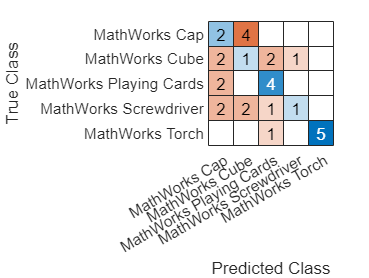

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% We acquire this so that we can compare overall brightness values between|
% the testing and training images and make a prediction based on how close|
% the overall brightness is between the images                            |
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Using the KNN classifier to predict the class of the numeric data by
% calculating the shortest distance between them. In this case, the 3
% closest data points are being used.
m_knn = knn_fit(train_examples,train_labels,3);
predictions = knn_predict(m_knn,test_examples);

% Test the accuracy of the prediction using a confusion matrix
% Easier than comparing the data individually 
[c,order] = confusionmat(test_labels,predictions);

% Visual representation of the confusion matrix - easier to deal with
confusionchart(test_labels,predictions)


% Calculates overall accuracy of the predictions to show how efficient the
% training is.
p = sum(diag(c))/sum(c(1:1:end))

p = 0.4333

## 3. Edge-based features

% add your code and comments below:
rng(0); % re-seed the random number for reproducible results

% Loads the merchdata dataset, includes the images in the subfolders and
% also the name of the folders - categorising them as labels.
imds = imageDatastore('MerchData', ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

% Calling surf so that I can visualise the change in gradient and steep
% slopes. Makes is easier for me to understand what I am working with.
im = training.readimage(1);
im = my_im2gray(im);

R = 227×227
   163   163   163   164   164   165   165   165   164   164   164   164   164   164   164   164   165   165   164   163   163   162   161   161   161   161   161   161   161   161
   163   163   163   164   164   164   165   165   164   164   164   164   164   164   164   164   165   165   164   163   163   162   161   161   161   161   161   161   161   161
   163   163   163   163   164   164   164   165   164   164   164   164   164   164   164   164   165   165   164   163   163   162   161   161   161   161   161   161   161   161
   162   162   163   163   163   164   164   164   164   164   164   164   164   164   164   164   165   165   164   163   163   162   161   161   161   161   161   161   161   161
   162   162   162   163   163   163   164   164   164   164   164   164   164   164   164   164   165   165   164   163   163   162   161   161   161   161   161   161   161   161
   161   162   162   162   163   163   163   163   164   164   164   164   164   16

G = 227×227
   178   178   178   179   179   180   180   180   179   179   179   179   179   179   179   179   179   179   178   177   177   176   175   175   175   175   175   175   175   175
   178   178   178   179   179   179   180   180   179   179   179   179   179   179   179   179   179   179   178   177   177   176   175   175   175   175   175   175   175   175
   178   178   178   178   179   179   179   180   179   179   179   179   179   179   179   179   179   179   178   177   177   176   175   175   175   175   175   175   175   175
   177   177   178   178   178   179   179   179   179   179   179   179   179   179   179   179   179   179   178   177   177   176   175   175   175   175   175   175   175   175
   177   177   177   178   178   178   179   179   179   179   179   179   179   179   179   179   179   179   178   177   177   176   175   175   175   175   175   175   175   175
   176   177   177   177   178   178   178   178   179   179   179   179   179   17

B = 227×227
   207   207   207   208   208   209   209   209   208   208   208   208   208   208   208   208   208   208   207   206   206   205   204   204   204   204   204   204   204   204
   207   207   207   208   208   208   209   209   208   208   208   208   208   208   208   208   208   208   207   206   206   205   204   204   204   204   204   204   204   204
   207   207   207   207   208   208   208   209   208   208   208   208   208   208   208   208   208   208   207   206   206   205   204   204   204   204   204   204   204   204
   206   206   207   207   207   208   208   208   208   208   208   208   208   208   208   208   208   208   207   206   206   205   204   204   204   204   204   204   204   204
   206   206   206   207   207   207   208   208   208   208   208   208   208   208   208   208   208   208   207   206   206   205   204   204   204   204   204   204   204   204
   205   206   206   206   207   207   207   207   208   208   208   208   208   20

im_g = 227×227
   177   177   177   178   178   179   179   179   178   178   178   178   178   178   178   178   178   178   177   176   176   174   174   174   174   174   174   174   174   174
   177   177   177   178   178   178   179   179   178   178   178   178   178   178   178   178   178   178   177   176   176   174   174   174   174   174   174   174   174   174
   177   177   177   177   178   178   178   179   178   178   178   178   178   178   178   178   178   178   177   176   176   174   174   174   174   174   174   174   174   174
   175   175   177   177   177   178   178   178   178   178   178   178   178   178   178   178   178   178   177   176   176   174   174   174   174   174   174   174   174   174
   175   175   175   177   177   177   178   178   178   178   178   178   178   178   178   178   178   178   177   176   176   174   174   174   174   174   174   174   174   174
   174   175   175   175   177   177   177   177   178   178   178   178   178  

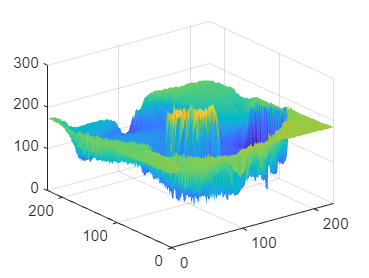

surf(im,'EdgeColor', 'none')


% Shuffles and splits the data into training and testing data so that we
% can get fair results when making predictions 

% 60% should be for training as it will allow the computer to make a better
% assumption when being asked to make predictions.
% 40% of the data should be for testing - to of course test the computer
[training, testing] = splitEachLabel(imds, 0.6, 'randomize');

% Acquire the class labels from training data which allow us to tell the
% difference between each row of data
train_labels = training.Labels;

% Gets edge values of each training image by passing it through the 
% get_edges function.
train_examples = [];
while hasdata(training)
    im = my_im2gray(training.read());
    train_examples(end+1,:) = get_edges(im);
end

R = 227×227
   163   163   163   164   164   165   165   165   164   164   164   164   164   164   164   164   165   165   164   163   163   162   161   161   161   161   161   161   161   161
   163   163   163   164   164   164   165   165   164   164   164   164   164   164   164   164   165   165   164   163   163   162   161   161   161   161   161   161   161   161
   163   163   163   163   164   164   164   165   164   164   164   164   164   164   164   164   165   165   164   163   163   162   161   161   161   161   161   161   161   161
   162   162   163   163   163   164   164   164   164   164   164   164   164   164   164   164   165   165   164   163   163   162   161   161   161   161   161   161   161   161
   162   162   162   163   163   163   164   164   164   164   164   164   164   164   164   164   165   165   164   163   163   162   161   161   161   161   161   161   161   161
   161   162   162   162   163   163   163   163   164   164   164   164   164   16

G = 227×227
   178   178   178   179   179   180   180   180   179   179   179   179   179   179   179   179   179   179   178   177   177   176   175   175   175   175   175   175   175   175
   178   178   178   179   179   179   180   180   179   179   179   179   179   179   179   179   179   179   178   177   177   176   175   175   175   175   175   175   175   175
   178   178   178   178   179   179   179   180   179   179   179   179   179   179   179   179   179   179   178   177   177   176   175   175   175   175   175   175   175   175
   177   177   178   178   178   179   179   179   179   179   179   179   179   179   179   179   179   179   178   177   177   176   175   175   175   175   175   175   175   175
   177   177   177   178   178   178   179   179   179   179   179   179   179   179   179   179   179   179   178   177   177   176   175   175   175   175   175   175   175   175
   176   177   177   177   178   178   178   178   179   179   179   179   179   17

B = 227×227
   207   207   207   208   208   209   209   209   208   208   208   208   208   208   208   208   208   208   207   206   206   205   204   204   204   204   204   204   204   204
   207   207   207   208   208   208   209   209   208   208   208   208   208   208   208   208   208   208   207   206   206   205   204   204   204   204   204   204   204   204
   207   207   207   207   208   208   208   209   208   208   208   208   208   208   208   208   208   208   207   206   206   205   204   204   204   204   204   204   204   204
   206   206   207   207   207   208   208   208   208   208   208   208   208   208   208   208   208   208   207   206   206   205   204   204   204   204   204   204   204   204
   206   206   206   207   207   207   208   208   208   208   208   208   208   208   208   208   208   208   207   206   206   205   204   204   204   204   204   204   204   204
   205   206   206   206   207   207   207   207   208   208   208   208   208   20

im_g = 227×227
   177   177   177   178   178   179   179   179   178   178   178   178   178   178   178   178   178   178   177   176   176   174   174   174   174   174   174   174   174   174
   177   177   177   178   178   178   179   179   178   178   178   178   178   178   178   178   178   178   177   176   176   174   174   174   174   174   174   174   174   174
   177   177   177   177   178   178   178   179   178   178   178   178   178   178   178   178   178   178   177   176   176   174   174   174   174   174   174   174   174   174
   175   175   177   177   177   178   178   178   178   178   178   178   178   178   178   178   178   178   177   176   176   174   174   174   174   174   174   174   174   174
   175   175   175   177   177   177   178   178   178   178   178   178   178   178   178   178   178   178   177   176   176   174   174   174   174   174   174   174   174   174
   174   175   175   175   177   177   177   177   178   178   178   178   178  

fraction_x = 0.0766

fraction_y = 0.0774

R = 227×227
   146   145   144   142   141   139   138   137   136   135   133   132   131   131   132   133   128   129   129   130   130   131   131   132   126   126   126   126   126   126
   136   135   135   135   135   135   134   134   131   131   130   129   129   130   132   132   131   131   131   131   131   132   132   132   131   131   131   131   131   131
   125   126   127   128   129   130   131   132   130   129   129   129   130   131   133   133   133   132   132   132   132   132   131   131   135   135   135   135   135   135
   125   125   126   127   129   130   131   132   133   133   133   133   133   133   134   134   131   131   131   130   129   129   128   128   131   131   131   131   131   131
   131   131   131   131   132   132   132   132   134   134   134   133   132   131   130   129   127   126   126   125   125   124   124   123   126   126   126   126   126   126
   135   135   134   133   132   131   130   130   129   129   129   128   126   12

G = 227×227
   126   125   124   122   121   119   118   117   115   114   112   111   110   110   111   112   109   110   110   111   111   112   112   113   107   107   107   107   107   107
   116   115   115   115   115   115   114   114   110   110   109   108   108   109   111   111   112   112   112   112   112   113   113   113   112   112   112   112   112   112
   105   106   107   108   109   109   110   111   109   108   108   108   108   109   111   112   114   113   113   113   113   113   112   112   116   116   116   116   116   116
   104   104   105   106   108   109   110   111   112   112   112   111   111   111   112   112   111   112   111   111   109   110   108   109   111   112   111   112   111   112
   110   110   110   110   111   111   111   111   112   112   112   111   110   109   108   107   107   106   106   105   105   104   104   103   106   106   106   106   106   106
   113   113   112   111   110   109   108   108   107   107   107   106   104   10

B = 227×227
   53   52   51   49   50   48   49   48   48   47   47   46   47   47   48   47   41   41   41   42   42   43   43   44   38   38   38   38   38   38
   45   42   44   44   44   46   45   45   43   43   44   43   45   46   48   48   44   43   44   43   44   44   45   44   44   43   44   43   44   43
   36   35   38   39   40   42   43   44   44   43   45   45   48   49   51   49   48   45   47   45   47   45   46   44   50   48   50   48   50   48
   37   37   38   39   43   44   45   46   49   49   49   51   51   51   54   52   48   46   48   45   46   44   45   43   48   46   48   46   48   46
   45   45   45   45   48   48   48   48   52   52   52   53   52   51   51   49   46   43   45   42   44   41   43   40   45   43   45   43   45   43
   53   53   52   51   50   51   50   50   49   49   50   49   47   45   43   42   42   42   41   41   41   41   40   40   44   44   44   44   44   44
   52   51   50   49   47   47   46   45   43   43   45   45   44   42   41   39  

im_g = 227×227
   124   122   122   120   119   117   116   115   114   112   111   109   109   109   109   111   107   109   109   109   109   110   110   110   105   105   105   105   105   105
   114   113   113   113   113   113   112   112   109   109   108   107   107   108   109   109   110   110   110   110   110   110   110   110   110   110   110   110   110   110
   103   104   105   105   108   108   109   109   108   107   107   107   107   109   111   112   112   110   110   110   110   110   110   110   114   113   114   113   114   113
   102   102   104   104   107   108   109   109   112   112   112   111   111   111   112   112   109   110   109   109   108   109   106   107   109   110   109   110   109   110
   109   109   109   109   109   109   109   109   112   112   112   111   110   109   108   108   106   105   105   104   104   103   103   102   105   105   105   105   105   105
   112   112   112   111   110   109   108   108   108   108   108   106   104  

fraction_x = 0.0179

fraction_y = 0.0312

R = 227×227
   203   203   203   203   202   202   202   202   200   200   200   199   199   199   199   197   198   194   194   193   193   193   194   195   199   196   194   192   193   194
   199   199   199   199   199   199   199   199   201   201   201   200   200   200   200   198   191   190   193   197   198   197   196   195   200   201   201   204   205   206
   200   200   201   201   201   201   201   201   202   202   202   203   203   203   203   202   193   194   195   197   197   199   199   200   201   201   204   207   207   203
   203   203   203   203   204   204   204   206   205   205   206   207   207   207   208   207   207   204   201   198   198   201   206   210   214   213   211   209   203   197
   202   202   203   203   204   204   205   206   204   205   207   208   208   209   209   209   211   211   210   209   210   211   215   217   223   219   213   206   199   192
   193   192   194   194   195   196   198   199   200   201   201   202   204   20

G = 227×227
   203   204   204   204   204   204   204   205   205   205   205   204   203   203   202   205   212   213   210   209   207   207   207   208   208   206   203   202   204   206
   202   202   203   203   203   204   204   204   206   206   206   205   204   204   204   206   204   206   209   210   210   208   207   206   209   208   208   211   213   215
   206   206   207   207   207   207   207   208   208   209   209   210   209   209   209   210   206   207   207   208   207   206   207   206   206   207   208   210   211   208
   214   214   214   214   215   215   215   214   213   213   212   214   214   214   215   215   217   214   208   206   204   206   209   213   215   213   211   207   202   195
   215   215   216   215   216   216   217   216   214   215   215   216   217   219   219   218   218   216   214   214   213   214   215   217   220   214   206   198   190   180
   209   209   209   209   209   210   209   210   209   210   212   213   213   21

B = 227×227
   237   235   235   232   229   225   225   224   224   224   227   226   230   230   233   228   225   220   223   225   233   236   241   243   247   242   236   229   226   222
   233   233   232   230   228   226   224   223   226   226   226   227   229   231   231   229   220   219   224   229   234   236   237   238   240   237   234   230   226   224
   232   232   233   231   229   229   229   227   230   228   228   229   231   231   231   231   225   226   229   230   232   232   230   228   226   221   219   215   210   201
   234   234   236   236   237   237   237   237   236   236   234   233   233   232   233   234   242   241   234   229   226   225   224   222   219   211   203   194   182   172
   232   232   235   237   240   240   243   243   241   240   238   235   234   231   231   235   246   246   241   234   228   221   215   209   205   192   177   162   151   138
   225   225   228   232   235   237   239   240   240   239   234   231   228   22

im_g = 227×227
   207   208   208   207   206   206   206   206   206   206   206   205   204   204   205   205   209   208   206   207   207   207   207   208   209   208   204   202   204   204
   205   205   204   204   204   205   205   204   207   207   207   206   206   206   206   206   202   203   207   208   209   208   208   206   210   209   209   211   212   214
   207   207   209   208   208   208   208   208   208   209   209   210   210   210   210   209   205   206   206   207   207   206   207   207   207   207   208   210   210   206
   214   214   214   214   214   214   214   215   213   213   213   215   215   214   215   215   217   214   209   206   205   207   211   213   215   213   210   206   201   193
   212   212   215   214   215   215   216   217   214   214   215   216   216   217   217   217   219   218   216   215   214   214   215   216   219   213   205   196   188   179
   207   206   207   207   208   209   209   209   210   210   211   211   212  

fraction_x = 0.0250

fraction_y = 0.0744

R = 227×227
   164   169   170   166   163   164   164   162   160   161   161   162   162   161   161   160   162   161   159   158   158   159   161   162   158   159   159   160   160   159
   163   168   169   165   163   164   164   161   160   161   161   162   162   161   161   160   161   160   159   159   159   159   160   161   158   159   159   160   160   159
   162   166   168   164   162   163   163   160   160   160   161   161   161   161   160   160   160   160   159   159   159   159   160   160   158   159   159   160   160   159
   160   164   166   162   160   162   162   159   159   160   161   161   161   161   160   159   160   159   159   159   159   159   159   160   158   159   159   160   160   159
   157   162   164   160   159   160   160   158   159   159   160   161   161   160   159   159   158   159   159   159   159   159   159   158   158   159   159   160   160   159
   155   160   162   159   157   159   159   157   159   159   160   160   160   16

G = 227×227
   128   133   134   130   127   128   128   126   124   125   125   126   126   125   125   124   126   125   123   122   122   123   125   126   122   123   123   124   124   123
   127   132   133   129   127   128   128   125   124   125   125   126   126   125   125   124   125   124   123   123   123   123   124   125   122   123   123   124   124   123
   126   130   132   128   126   127   127   124   124   124   125   125   125   125   124   124   124   124   123   123   123   123   124   124   122   123   123   124   124   123
   124   128   130   126   124   126   126   123   123   124   125   125   125   125   124   123   124   123   123   123   123   123   123   124   122   123   123   124   124   123
   121   126   128   124   123   124   124   122   123   123   124   125   125   124   123   123   122   123   123   123   123   123   123   122   122   123   123   124   124   123
   119   124   126   123   121   123   123   121   123   123   124   124   124   12

B = 227×227
   52   57   58   54   51   52   52   50   48   49   49   50   50   49   49   48   50   49   47   46   46   47   49   50   46   47   47   48   48   47
   51   56   57   53   51   52   52   49   48   49   49   50   50   49   49   48   49   48   47   47   47   47   48   49   46   47   47   48   48   47
   50   54   56   52   50   51   51   48   48   48   49   49   49   49   48   48   48   48   47   47   47   47   48   48   46   47   47   48   48   47
   48   52   54   50   48   50   50   47   47   48   49   49   49   49   48   47   48   47   47   47   47   47   47   48   46   47   47   48   48   47
   45   50   52   48   47   48   48   46   47   47   48   49   49   48   47   47   46   47   47   47   47   47   47   46   46   47   47   48   48   47
   43   48   50   47   45   47   47   45   47   47   48   48   48   48   47   47   46   46   47   47   47   47   46   46   46   47   47   48   48   47
   42   47   49   46   44   46   47   45   46   47   47   48   48   47   47   46  

im_g = 227×227
   130   135   137   132   130   130   130   128   126   127   127   128   128   127   127   126   128   127   125   124   124   125   127   128   124   125   125   126   126   125
   130   133   135   131   130   130   130   127   126   127   127   128   128   127   127   126   127   126   125   125   125   125   126   127   124   125   125   126   126   125
   128   132   133   130   128   130   130   126   126   126   127   127   127   127   126   126   126   126   125   125   125   125   126   126   124   125   125   126   126   125
   126   130   132   128   126   128   128   125   125   126   127   127   127   127   126   125   126   125   125   125   125   125   125   126   124   125   125   126   126   125
   123   128   130   126   125   126   126   124   125   125   126   127   127   126   125   125   124   125   125   125   125   125   125   124   124   125   125   126   126   125
   121   126   128   125   123   125   125   123   125   125   126   126   126  

fraction_x = 0.0386

fraction_y = 0.0591

R = 227×227
   113   128   142   144   147   149   150   147   151   152   158   162   166   167   164   161   148   127   134   147   140   143   152   145   145   143   143   144   138   133
   121   132   141   141   141   144   146   145   148   149   153   159   163   164   161   157   148   123   125   140   139   141   148   144   144   142   142   143   139   134
   131   137   141   137   137   138   141   142   144   145   149   153   158   158   157   153   147   117   111   129   135   137   141   140   138   137   137   139   135   132
   137   139   140   138   137   136   138   139   140   143   147   150   155   155   153   150   144   112    98   114   130   134   134   135   130   129   130   133   130   126
   136   137   140   140   141   137   137   138   139   140   144   148   152   151   150   147   141   111    88    98   123   132   130   131   125   124   126   129   128   125
   134   133   137   141   142   137   135   135   138   139   143   147   150   15

G = 227×227
    95   110   123   126   127   130   130   127   127   128   129   133   135   136   132   131   118   100   107   120   113   116   125   118   120   118   118   119   116   111
   103   114   122   123   121   125   126   125   124   125   127   130   132   133   129   127   118    96    98   113   112   114   121   117   119   117   117   118   117   112
   113   119   122   119   117   119   121   122   120   121   123   127   129   128   125   123   117    90    84   102   110   112   116   115   113   112   112   114   113   110
   119   122   122   120   117   117   118   119   119   119   121   124   126   125   121   120   116    85    71    87   105   109   109   110   105   104   105   108   108   104
   119   120   122   123   122   118   117   118   118   119   120   124   126   124   120   117   113    85    62    72    97   106   105   106   100    99   101   104   103   100
   117   116   119   124   123   118   115   115   117   118   119   123   124   12

B = 227×227
   59   72   81   80   76   74   71   64   65   64   69   75   80   82   83   79   66   45   52   65   60   63   72   65   66   64   62   63   58   53
   67   76   80   75   70   69   67   62   60   61   66   72   77   79   80   77   66   41   43   58   59   61   68   64   65   63   61   62   59   54
   75   79   79   71   66   61   60   59   56   57   62   68   73   74   76   73   65   37   31   49   56   58   62   61   59   58   56   58   55   52
   79   79   76   70   64   59   57   56   54   55   60   65   70   71   70   70   66   32   18   34   51   55   55   56   51   50   49   52   50   46
   76   76   74   71   66   59   56   55   53   54   58   64   69   69   68   67   63   34   11   21   46   55   51   52   44   43   45   48   47   44
   73   70   69   72   67   59   54   52   54   53   57   63   67   67   66   65   61   40   10    7   37   54   48   45   43   42   44   47   47   44
   71   66   65   66   64   56   51   50   53   53   57   61   65   64   64   63  

im_g = 227×227
    97   111   123   126   128   129   129   126   127   127   131   135   138   139   135   134   121   102   109   121   115   118   126   119   121   119   119   120   116   111
   104   115   123   123   121   124   126   123   124   125   129   132   135   136   133   131   121    98   100   115   115   116   123   119   120   118   118   119   118   112
   114   120   123   119   118   118   120   121   119   120   124   129   131   130   129   126   120    92    86   105   111   114   117   117   114   114   113   116   112   110
   120   123   123   119   117   117   116   118   118   119   122   125   128   127   125   123   119    87    73    89   107   110   110   111   107   106   107   109   108   104
   120   120   122   122   122   117   116   116   117   118   120   124   127   126   123   121   115    87    63    73    99   107   107   107   101   100   102   105   103   101
   117   116   119   123   122   117   114   114   116   117   119   123   126  

fraction_x = 0.0345

fraction_y = 0.0413

R = 227×227
   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   175   174   172   171   170   171
   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   174   173   172   170   170   170
   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   172   171   170   170   170
   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   172   172   171   171   170   170
   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   173   172   172   172   172   171   171
   173   173   173   173   173   173   173   173   173   173   173   173   173   17

G = 227×227
   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   201   200   198   197   196   197
   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   200   199   198   196   196   196
   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   198   197   196   196   196
   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   198   198   197   197   196   196
   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   199   198   198   198   198   197   197
   199   199   199   199   199   199   199   199   199   199   199   199   199   19

B = 227×227
   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   238   237   235   234   233   234
   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   237   236   235   233   233   233
   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   235   234   233   233   233
   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   235   235   234   234   233   233
   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   236   235   235   235   235   234   234
   236   236   236   236   236   236   236   236   236   236   236   236   236   23

im_g = 227×227
   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   197   196   194   194   193   194
   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   194   193   193   193
   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   194   194   193   193   193
   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   194   194   194   194   193   193
   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   194   194   194   194   194   194
   196   196   196   196   196   196   196   196   196   196   196   196   196  

fraction_x = 0.0342

fraction_y = 0.0435

R = 227×227
   163   162   161   161   160   159   158   158   158   157   156   154   154   154   154   156   155   156   157   157   158   158   159   159   157   156   156   156   158   161
   164   161   163   160   161   158   160   157   158   155   156   153   155   153   155   155   158   159   159   159   160   160   161   161   161   160   160   160   161   164
   164   163   163   161   162   160   161   159   158   157   157   155   156   155   157   157   162   163   163   163   164   164   164   164   166   166   165   165   166   168
   166   164   165   163   164   162   164   161   162   160   161   159   161   160   163   163   168   168   168   168   168   168   168   168   171   170   169   169   169   170
   168   167   168   167   168   166   167   166   168   166   167   166   168   168   170   171   173   172   172   172   172   172   172   172   172   172   172   172   172   172
   172   171   172   171   172   171   172   171   173   172   173   173   175   17

G = 227×227
   186   185   184   184   183   182   181   181   181   180   179   177   177   177   177   176   171   170   171   171   172   172   173   173   171   170   170   170   172   175
   184   184   183   183   181   181   180   180   178   178   176   176   175   176   175   175   174   173   173   173   174   174   175   175   175   174   174   174   175   178
   183   184   182   182   181   181   180   180   177   178   176   176   175   176   176   176   178   178   178   178   179   179   179   179   181   181   180   180   181   183
   182   183   181   182   180   181   180   180   178   179   177   178   177   179   179   180   183   183   183   183   183   183   183   183   186   185   184   184   184   185
   183   184   183   184   183   183   182   183   183   183   182   183   183   185   185   186   188   187   187   187   187   187   187   187   187   187   187   187   187   187
   186   187   186   187   186   187   186   187   187   188   187   189   189   19

B = 227×227
   218   217   216   216   215   214   213   213   213   212   211   209   209   209   209   209   205   205   206   206   207   207   208   208   206   205   205   205   207   210
   217   216   216   215   214   213   213   212   211   210   209   208   208   208   208   208   208   208   208   208   209   209   210   210   210   209   209   209   210   213
   215   215   214   213   213   212   212   211   209   209   208   207   207   207   208   208   211   211   211   211   212   212   212   212   214   214   213   213   214   216
   215   213   214   212   213   211   213   210   211   209   210   208   210   209   212   210   216   214   216   214   216   214   216   214   219   216   217   215   217   216
   214   212   214   212   214   211   213   211   214   211   213   211   214   213   216   215   219   216   218   216   218   216   218   216   218   216   218   216   218   216
   215   213   215   213   215   213   215   213   216   214   216   215   218   21

im_g = 227×227
   183   182   181   181   180   179   177   177   177   177   176   174   174   174   174   174   169   170   170   170   172   172   174   174   170   170   170   170   172   175
   182   181   181   180   178   177   178   177   175   174   174   173   173   173   173   173   173   174   174   174   174   174   175   175   175   174   174   174   175   177
   181   182   180   179   178   178   178   178   175   175   174   173   174   173   174   174   176   177   177   177   178   178   178   178   180   180   179   179   180   182
   182   180   179   180   179   178   179   178   176   177   176   176   176   177   178   179   182   181   182   181   182   181   182   181   185   185   184   184   184   185
   181   182   181   182   181   181   181   181   181   181   181   181   181   183   185   185   187   186   186   186   186   186   186   186   186   186   186   186   186   186
   185   185   185   185   185   185   185   185   187   185   187   188   188  

fraction_x = 0.0610

fraction_y = 0.0712

R = 227×227
   168   168   168   168   168   168   168   168   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   168   168   166   165   165   165
   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   168   167   166   166   165   165
   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   169   168   167   167   166   165   166
   170   170   170   170   170   170   170   170   169   169   169   169   169   169   169   169   168   168   168   168   168   168   168   168   168   167   167   166   166   166
   170   170   170   170   170   170   170   170   169   169   169   169   169   169   169   169   168   168   168   168   168   168   168   168   168   167   167   166   166   167
   169   169   169   169   169   169   169   169   169   169   169   169   169   16

G = 227×227
   183   183   183   183   183   183   183   183   184   184   184   184   184   184   184   184   185   185   185   185   185   185   185   185   184   184   182   181   181   181
   184   184   184   184   184   184   184   184   184   184   184   184   184   184   184   184   185   185   185   185   185   185   185   185   184   183   182   182   181   181
   184   184   184   184   184   184   184   184   184   184   184   184   184   184   184   184   185   185   185   185   185   185   185   185   184   183   183   182   181   182
   185   185   185   185   185   185   185   185   184   184   184   184   184   184   184   183   184   184   184   184   184   184   184   184   184   183   183   182   182   182
   184   184   184   184   184   184   184   184   183   183   183   183   183   183   183   183   184   184   184   184   184   184   184   184   184   183   183   182   182   183
   183   183   183   183   183   183   183   183   183   183   183   183   183   18

B = 227×227
   206   206   206   206   206   206   206   206   207   207   207   207   207   207   207   207   211   211   211   211   211   211   211   211   210   210   208   207   207   207
   207   207   207   207   207   207   207   207   207   207   207   207   207   207   207   207   211   211   211   211   211   211   211   211   210   209   208   208   207   207
   207   207   207   207   207   207   207   207   207   207   207   207   207   207   207   207   211   211   211   211   211   211   211   211   210   209   209   208   207   208
   208   208   208   208   208   208   208   208   207   207   207   207   207   207   207   209   210   210   210   210   210   210   210   210   210   209   209   208   208   208
   210   210   210   210   210   210   210   210   209   209   209   209   209   209   209   209   210   210   210   210   210   210   210   210   210   209   209   208   208   209
   209   209   209   209   209   209   209   209   209   209   209   209   209   20

im_g = 227×227
   180   180   180   180   180   180   180   180   183   183   183   183   183   183   183   183   184   184   184   184   184   184   184   184   182   182   181   179   179   179
   183   183   183   183   183   183   183   183   183   183   183   183   183   183   183   183   184   184   184   184   184   184   184   184   182   181   181   181   179   179
   183   183   183   183   183   183   183   183   183   183   183   183   183   183   183   183   184   184   184   184   184   184   184   184   182   181   181   181   179   181
   184   184   184   184   184   184   184   184   183   183   183   183   183   183   183   182   182   182   182   182   182   182   182   182   182   181   181   181   181   181
   183   183   183   183   183   183   183   183   182   182   182   182   182   182   182   182   182   182   182   182   182   182   182   182   182   181   181   181   181   181
   182   182   182   182   182   182   182   182   182   182   182   182   182  

fraction_x = 0.0470

fraction_y = 0.0730

R = 227×227
   181   181   181   181   183   183   183   183   179   182   189   187   177   181   185   176   184   198   188   188   203   186   169   186   173   170   167   168   173   175
   181   181   181   181   183   183   183   183   187   182   182   182   176   182   187   182   166   195   195   178   177   173   166   172   176   175   173   172   171   170
   180   180   180   180   181   181   181   181   188   177   178   183   178   180   184   180   183   189   185   171   163   161   164   169   180   180   178   174   169   164
   180   178   180   180   180   180   181   181   184   174   180   189   182   178   178   177   211   173   155   166   168   158   164   176   184   181   176   172   168   165
   178   177   178   178   178   178   180   180   180   174   183   189   182   180   184   184   192   152   139   160   169   166   170   178   184   177   169   167   169   170
   177   177   177   177   177   178   178   178   182   178   183   182   178   18

G = 227×227
   189   189   190   192   191   192   192   191   187   189   198   197   189   193   198   187   189   199   186   182   193   172   148   163   148   144   140   142   149   153
   189   190   190   192   191   192   192   191   195   189   191   191   188   194   200   193   172   197   194   173   166   157   146   149   152   149   146   146   146   145
   190   191   191   192   192   193   193   192   198   187   187   192   190   192   197   192   190   193   185   169   154   147   145   148   156   155   151   147   144   139
   190   192   192   192   193   193   193   192   194   183   189   198   194   190   191   187   221   177   157   164   159   146   147   156   161   156   149   145   143   139
   191   193   193   193   194   194   193   193   192   185   192   198   192   191   196   194   200   158   141   157   162   154   153   157   162   153   143   140   143   144
   193   193   194   194   195   194   194   193   194   189   192   191   189   19

B = 227×227
   226   225   219   214   210   207   209   210   210   215   227   224   215   215   217   207   219   229   208   196   194   163   127   131   108    95    87    85    89    93
   226   223   219   214   210   207   209   210   218   217   220   220   214   216   219   211   194   218   208   179   162   142   121   115   108   100    91    89    89    88
   225   223   219   214   210   209   209   210   223   214   216   221   216   214   214   206   198   196   183   157   137   120   112   105   108   101    96    92    88    85
   225   221   218   214   210   209   209   210   219   212   220   227   220   212   208   196   213   162   136   139   128   108   103   106   107   100    94    90    89    88
   223   219   216   212   209   209   209   212   218   213   223   227   217   211   212   196   179   124   104   116   116   104    99   100   104    93    86    85    92    95
   219   218   214   210   209   209   210   212   220   217   223   220   211   21

im_g = 227×227
   191   191   191   191   191   192   192   191   188   190   198   198   189   192   196   187   191   202   189   185   196   176   152   167   151   147   142   143   149   153
   191   191   191   191   191   192   192   191   195   190   191   191   187   193   198   191   173   199   196   175   168   160   150   151   154   150   148   147   147   146
   192   191   191   191   191   191   191   191   197   187   188   193   190   191   195   190   190   191   185   168   155   148   147   150   158   157   153   148   146   141
   192   191   192   191   191   191   191   191   194   183   190   198   193   189   189   185   217   174   154   162   158   145   147   157   162   157   151   146   144   141
   190   191   191   190   191   191   191   191   192   185   193   198   192   190   194   191   194   152   137   153   159   152   152   156   162   154   145   142   145   147
   191   191   191   191   191   191   191   190   193   189   193   191   188  

fraction_x = 0.0358

fraction_y = 0.0512

R = 227×227
   127   127   126   125   125   124   123   123   124   123   123   123   123   124   125   126   125   126   128   129   130   131   131   131   134   134   134   133   133   132
   127   127   126   125   124   124   123   123   124   123   123   123   123   124   125   126   125   126   128   129   130   131   131   131   134   134   134   133   133   132
   127   126   126   125   124   123   123   123   123   123   123   123   123   124   125   125   125   126   128   129   130   131   131   131   134   134   134   133   133   132
   126   126   125   125   124   123   122   122   123   123   122   122   123   123   124   125   125   126   128   129   130   131   131   131   134   134   134   133   133   132
   126   126   125   124   123   123   122   122   123   122   122   122   122   123   124   125   125   126   128   129   130   131   131   131   134   134   134   133   133   132
   125   125   125   124   123   122   122   121   122   122   121   121   122   12

G = 227×227
   130   130   129   128   128   127   126   126   127   126   126   126   126   127   128   129   128   129   131   132   133   134   134   134   137   137   137   136   136   135
   130   130   129   128   127   127   126   126   127   126   126   126   126   127   128   129   128   129   131   132   133   134   134   134   137   137   137   136   136   135
   130   129   129   128   127   126   126   126   126   126   126   126   126   127   128   128   128   129   131   132   133   134   134   134   137   137   137   136   136   135
   129   129   128   128   127   126   125   125   126   126   125   125   126   126   127   128   128   129   131   132   133   134   134   134   137   137   137   136   136   135
   129   129   128   127   126   126   125   125   126   125   125   125   125   126   127   128   128   129   131   132   133   134   134   134   137   137   137   136   136   135
   128   128   128   127   126   125   125   124   125   125   124   124   125   12

B = 227×227
   147   147   146   145   145   144   143   143   144   143   143   143   143   144   145   146   145   146   148   149   150   151   151   151   154   154   154   153   153   152
   147   147   146   145   144   144   143   143   144   143   143   143   143   144   145   146   145   146   148   149   150   151   151   151   154   154   154   153   153   152
   147   146   146   145   144   143   143   143   143   143   143   143   143   144   145   145   145   146   148   149   150   151   151   151   154   154   154   153   153   152
   146   146   145   145   144   143   142   142   143   143   142   142   143   143   144   145   145   146   148   149   150   151   151   151   154   154   154   153   153   152
   146   146   145   144   143   143   142   142   143   142   142   142   142   143   144   145   145   146   148   149   150   151   151   151   154   154   154   153   153   152
   145   145   145   144   143   142   142   141   142   142   141   141   142   14

im_g = 227×227
   131   131   131   129   129   128   127   127   128   127   127   127   127   128   129   131   129   131   132   133   134   135   135   135   138   138   138   137   137   135
   131   131   131   129   128   128   127   127   128   127   127   127   127   128   129   131   129   131   132   133   134   135   135   135   138   138   138   137   137   135
   131   131   131   129   128   127   127   127   127   127   127   127   127   128   129   129   129   131   132   133   134   135   135   135   138   138   138   137   137   135
   131   131   129   129   128   127   125   125   127   127   125   125   127   127   128   129   129   131   132   133   134   135   135   135   138   138   138   137   137   135
   131   131   129   128   127   127   125   125   127   125   125   125   125   127   128   129   129   131   132   133   134   135   135   135   138   138   138   137   137   135
   129   129   129   128   127   125   125   125   125   125   125   125   125  

fraction_x = 0.1055

fraction_y = 0.1399

R = 227×227
   134   135   135   136   136   135   135   134   135   135   135   136   136   137   137   137   137   138   138   139   139   138   138   137   139   139   139   140   140   141
   134   135   135   136   136   135   135   134   135   135   135   136   136   137   137   137   137   138   138   139   139   138   138   137   139   139   139   140   140   141
   134   135   135   136   136   135   135   134   135   135   135   136   136   137   137   137   137   138   138   139   139   138   138   137   139   139   139   140   140   141
   134   135   135   136   136   135   135   134   135   135   135   136   136   137   137   137   137   138   138   139   139   138   138   137   139   139   139   140   140   141
   134   135   135   136   136   135   135   134   135   135   135   136   136   137   137   137   137   138   138   139   139   138   138   137   139   139   139   140   140   141
   134   135   135   136   136   135   135   134   135   135   135   136   136   13

G = 227×227
   140   141   141   142   142   141   141   140   141   141   141   142   142   143   143   143   143   144   144   145   145   144   144   143   145   145   145   146   146   147
   140   141   141   142   142   141   141   140   141   141   141   142   142   143   143   143   143   144   144   145   145   144   144   143   145   145   145   146   146   147
   140   141   141   142   142   141   141   140   141   141   141   142   142   143   143   143   143   144   144   145   145   144   144   143   145   145   145   146   146   147
   140   141   141   142   142   141   141   140   141   141   141   142   142   143   143   143   143   144   144   145   145   144   144   143   145   145   145   146   146   147
   140   141   141   142   142   141   141   140   141   141   141   142   142   143   143   143   143   144   144   145   145   144   144   143   145   145   145   146   146   147
   140   141   141   142   142   141   141   140   141   141   141   142   142   14

B = 227×227
   176   177   177   178   178   177   177   176   177   177   177   178   178   179   179   179   179   180   180   181   181   180   180   179   181   181   181   182   182   183
   176   177   177   178   178   177   177   176   177   177   177   178   178   179   179   179   179   180   180   181   181   180   180   179   181   181   181   182   182   183
   176   177   177   178   178   177   177   176   177   177   177   178   178   179   179   179   179   180   180   181   181   180   180   179   181   181   181   182   182   183
   176   177   177   178   178   177   177   176   177   177   177   178   178   179   179   179   179   180   180   181   181   180   180   179   181   181   181   182   182   183
   176   177   177   178   178   177   177   176   177   177   177   178   178   179   179   179   179   180   180   181   181   180   180   179   181   181   181   182   182   183
   176   177   177   178   178   177   177   176   177   177   177   178   178   17

im_g = 227×227
   142   143   143   144   144   143   143   142   143   143   143   144   144   145   145   145   145   147   147   148   148   147   147   145   148   148   148   149   149   149
   142   143   143   144   144   143   143   142   143   143   143   144   144   145   145   145   145   147   147   148   148   147   147   145   148   148   148   149   149   149
   142   143   143   144   144   143   143   142   143   143   143   144   144   145   145   145   145   147   147   148   148   147   147   145   148   148   148   149   149   149
   142   143   143   144   144   143   143   142   143   143   143   144   144   145   145   145   145   147   147   148   148   147   147   145   148   148   148   149   149   149
   142   143   143   144   144   143   143   142   143   143   143   144   144   145   145   145   145   147   147   148   148   147   147   145   148   148   148   149   149   149
   142   143   143   144   144   143   143   142   143   143   143   144   144  

fraction_x = 0.1229

fraction_y = 0.1151

R = 227×227
   130   131   132   134   137   139   140   141   139   140   141   143   145   148   149   150   155   156   157   158   159   161   162   162   161   161   161   162   162   162
   132   133   135   137   139   141   142   143   143   144   145   147   149   151   153   154   157   157   158   159   161   162   163   163   163   163   163   163   164   164
   136   137   138   140   142   144   145   146   148   149   151   152   154   156   158   158   159   160   160   162   163   164   165   165   164   165   165   165   166   166
   141   141   143   144   146   148   149   150   153   154   155   156   158   160   161   162   162   162   163   164   165   166   166   167   165   165   165   166   166   167
   145   146   147   148   150   151   152   153   155   156   157   158   160   161   163   163   164   164   165   166   166   167   167   168   165   165   165   166   166   167
   148   149   150   151   152   154   155   155   157   158   159   160   161   16

G = 227×227
   132   133   134   136   139   141   142   143   141   142   143   145   147   150   151   152   157   158   159   160   161   163   164   164   163   163   163   164   164   164
   134   135   137   139   141   143   144   145   145   146   147   149   151   153   155   156   159   159   160   161   163   164   165   165   165   165   165   165   166   166
   138   139   140   142   144   146   147   148   150   151   153   154   156   158   160   160   161   162   162   164   165   166   167   167   166   167   167   167   168   168
   143   143   145   146   148   150   151   152   155   156   157   158   160   162   163   164   164   164   165   166   167   168   168   169   167   167   167   168   168   169
   147   148   149   150   152   153   154   155   157   158   159   160   162   163   165   165   166   166   167   168   168   169   169   170   167   167   167   168   168   169
   150   151   152   153   154   156   157   157   159   160   161   162   163   16

B = 227×227
   147   148   149   151   154   156   157   158   156   157   158   160   162   165   166   165   170   170   171   172   173   175   176   176   175   175   175   176   176   176
   149   150   152   154   156   158   159   160   160   161   162   164   166   168   170   169   172   171   172   173   175   176   177   177   177   177   177   177   178   178
   153   154   155   157   159   161   162   163   165   166   168   169   171   173   175   173   174   174   174   176   177   178   179   179   178   179   179   179   180   180
   158   158   160   161   163   165   166   167   170   171   172   173   175   177   178   177   177   176   177   178   179   180   180   181   179   179   179   180   180   181
   162   163   164   165   167   168   169   170   172   173   174   175   177   178   180   178   179   178   179   180   180   181   181   182   179   179   179   180   180   181
   165   166   167   168   169   171   172   172   174   175   176   177   178   17

im_g = 227×227
   133   134   135   137   141   143   143   144   143   143   144   146   147   151   153   153   157   159   159   161   163   164   164   164   164   164   164   164   164   164
   135   136   137   141   143   144   145   146   146   147   147   150   153   154   156   157   160   159   161   163   164   164   166   166   166   166   166   166   166   166
   139   141   141   143   145   147   147   150   151   153   154   154   157   160   161   161   163   163   163   164   166   166   167   167   166   167   167   167   170   170
   144   144   146   147   150   151   153   153   156   157   158   160   161   163   164   164   164   164   166   166   167   170   170   170   167   167   167   170   170   170
   147   150   150   151   153   154   154   156   158   160   160   161   163   164   167   166   166   166   167   170   170   170   170   171   167   167   167   170   170   170
   151   153   153   154   154   157   158   158   160   161   163   163   164  

fraction_x = 0.0744

fraction_y = 0.1181

R = 227×227
   154   162   172   179   181   179   174   169   157   156   156   155   158   172   200   223   223   227   240   243   241   247   251   242   246   252   255   255   255   255
   154   158   167   173   179   182   185   184   188   185   182   178   172   179   209   238   249   231   232   238   237   241   247   247   253   250   248   248   254   255
   169   174   185   194   204   210   213   212   208   202   199   192   180   175   207   239   232   214   224   248   251   245   244   245   248   246   247   249   253   255
   187   192   203   211   213   210   202   193   181   174   174   172   160   153   174   205   205   207   235   255   255   249   248   248   236   245   254   255   251   249
   181   182   184   181   173   161   145   132   134   126   129   136   135   132   144   165   199   223   254   255   251   249   255   255   244   244   243   245   248   251
   164   159   152   145   138   131   121   112   107   101   106   116   125   13

G = 227×227
   156   158   158   156   152   153   158   163   163   169   170   167   160   166   185   205   213   221   233   239   236   244   247   236   239   241   242   239   235   233
   155   155   154   153   154   162   174   183   199   201   199   190   173   170   191   219   237   225   225   234   234   237   243   243   245   239   232   230   232   236
   169   172   175   180   187   198   212   222   226   224   221   206   178   163   181   212   215   204   216   242   246   240   239   239   240   236   232   232   232   234
   199   203   207   212   216   217   220   222   219   214   208   198   170   148   157   183   191   197   226   254   253   244   242   241   228   235   240   239   233   231
   217   216   213   210   205   199   193   190   198   192   188   184   167   149   149   162   190   211   244   255   243   243   252   254   236   233   231   230   233   236
   212   206   198   193   191   190   191   191   192   188   183   181   176   16

B = 227×227
   179   183   184   182   172   164   161   165   175   188   196   183   155   130   116   103    79    65    64    52    33    25    18     0     1     3     6     4     0     0
   173   172   172   165   157   153   154   162   185   198   206   190   157   127   117   114   103    69    57    51    35    24    21    12    14     7     0     0     0     0
   177   177   174   167   157   150   147   153   166   175   185   173   139   105    97   105    83    54    53    66    56    37    26    21    19    14     9     5     1     0
   185   186   184   178   163   147   134   130   136   144   157   151   118    82    69    72    60    50    71    88    75    56    46    39    23    26    29    22     9     0
   169   166   165   156   140   124   107   105   122   130   142   142   117    81    57    49    63    73    97   100    80    71    76    72    50    43    33    25    16     9
   128   125   123   117   113   108   105   108   124   133   147   149   135   10

im_g = 227×227
   158   162   165   167   163   163   163   166   163   167   169   165   159   163   182   199   201   205   216   219   215   220   222   211   214   216   219   216   214   213
   157   158   160   161   162   166   175   180   194   196   194   187   171   168   187   213   225   209   207   214   212   214   219   218   222   216   210   209   212   215
   170   173   178   183   189   196   205   210   214   211   210   198   174   160   179   207   204   190   200   224   225   218   216   215   217   215   211   211   212   213
   194   197   204   207   210   207   204   203   199   194   192   184   161   142   152   176   180   184   211   235   234   223   221   219   208   214   220   219   213   210
   200   200   199   195   188   179   168   163   170   166   165   165   151   135   136   150   178   199   230   237   227   225   233   233   218   215   213   211   213   215
   188   183   175   169   166   163   160   157   159   155   156   158   155  

fraction_x = 0.0980

fraction_y = 0.1043

R = 227×227
   196   194   171   130    97    87    88    86   109   150   193   213   220   227   229   225   228   222   227   238   246   247   249   255   254   252   248   250   255   255
   186   198   209   215   215   199   162   125    80    79    91   126   172   207   227   232   221   232   232   226   236   254   252   234   238   247   255   255   255   255
   201   207   211   211   218   226   226   218   176   137    94    76    79   101   141   177   213   239   249   234   228   245   255   254   255   255   251   247   245   249
   209   218   223   222   222   231   240   245   244   232   208   168   118    79    70    79   120   154   201   239   252   251   251   255   255   252   241   244   255   255
   221   226   234   244   251   249   237   223   229   241   248   241   222   190   149   118    93    86   102   145   194   224   242   253   254   251   248   252   254   240
   240   241   239   234   233   236   243   248   241   244   241   236   246   25

G = 227×227
   211   209   185   143   108    97    95    93   112   152   195   214   220   227   231   231   240   238   241   249   253   251   250   254   249   243   237   236   239   240
   200   212   222   227   226   209   168   132    85    81    93   127   172   210   229   238   233   245   244   235   242   255   251   231   232   238   244   243   241   239
   213   220   223   222   227   234   231   223   180   141    98    80    82   105   145   183   219   246   255   239   231   245   255   251   252   247   239   232   228   228
   221   230   234   231   230   238   246   249   246   235   211   174   123    86    76    85   123   155   202   238   249   247   248   253   255   242   227   227   235   239
   231   237   244   252   255   255   241   228   233   246   253   248   228   199   158   123    90    81    96   139   185   216   233   243   241   237   234   235   232   216
   249   247   244   240   237   239   245   251   244   247   245   242   251   25

B = 227×227
   192   188   160   115    74    60    54    51    69   112   156   180   192   203   209   203   200   189   190   191   185   166   146   125    95    64    33    13     3     0
   185   195   202   203   196   175   132    91    45    42    56    95   144   183   207   210   197   201   196   178   172   171   143    98    74    57    41    26    13     5
   209   213   213   206   206   210   201   191   145   106    63    47    53    78   120   157   191   212   214   185   160   155   139   112    88    64    41    25    16    15
   211   218   218   212   206   207   212   212   206   192   168   130    82    45    38    49    92   123   160   184   180   156   133   117    98    67    42    35    42    47
   204   207   210   215   216   207   190   172   174   182   189   181   164   134    95    65    45    39    48    81   116   131   128   120   100    79    65    61    60    45
   186   183   178   170   163   160   162   164   155   156   151   146   157   16

im_g = 227×227
   205   202   178   136   100    90    88    87   107   147   190   211   217   224   228   226   232   228   231   239   244   240   238   239   233   225   217   215   216   217
   194   205   215   220   219   202   162   124    79    77    88   124   168   206   226   233   225   236   234   226   233   245   238   217   215   220   224   222   218   217
   209   215   218   216   221   229   227   218   176   136    93    75    78   101   141   178   215   239   248   231   222   235   242   236   234   228   220   213   209   210
   216   225   229   226   224   233   240   243   240   229   205   167   116    79    70    80   118   151   197   232   242   238   236   238   237   225   210   210   219   221
   225   231   237   246   250   248   234   221   225   237   245   239   219   189   149   114    86    78    91   134   180   209   224   233   228   223   218   220   219   204
   239   238   234   230   228   229   235   240   233   236   233   230   239  

fraction_x = 0.1495

fraction_y = 0.1497

R = 227×227
   127   127   127   128   128   129   129   129   129   129   129   130   130   131   131   130   130   129   129   130   130   131   131   131   130   130   130   130   130   130
   127   127   127   128   128   128   129   129   129   129   129   130   130   131   131   130   130   129   129   130   130   131   131   131   130   130   130   130   130   130
   127   127   127   127   128   128   128   129   129   129   129   130   130   131   131   130   130   129   129   130   130   131   131   131   130   130   130   130   130   130
   126   126   127   127   127   128   128   128   129   129   129   130   130   131   131   130   130   129   129   130   130   131   131   131   130   130   130   130   130   130
   126   126   126   127   127   127   128   128   129   129   129   130   130   131   131   130   130   129   129   130   130   131   131   131   130   130   130   130   130   130
   125   126   126   126   127   127   127   127   129   129   129   130   130   13

G = 227×227
   130   130   130   131   131   132   132   132   132   132   132   133   133   134   134   134   134   135   135   136   136   137   137   137   136   136   136   136   136   136
   130   130   130   131   131   131   132   132   132   132   132   133   133   134   134   134   134   135   135   136   136   137   137   137   136   136   136   136   136   136
   130   130   130   130   131   131   131   132   132   132   132   133   133   134   134   134   134   135   135   136   136   137   137   137   136   136   136   136   136   136
   129   129   130   130   130   131   131   131   132   132   132   133   133   134   134   134   134   135   135   136   136   137   137   137   136   136   136   136   136   136
   129   129   129   130   130   130   131   131   132   132   132   133   133   134   134   134   134   135   135   136   136   137   137   137   136   136   136   136   136   136
   128   129   129   129   130   130   130   130   132   132   132   133   133   13

B = 227×227
   165   165   165   166   166   167   167   167   167   167   167   168   168   169   169   169   169   169   169   170   170   171   171   171   170   170   170   170   170   170
   165   165   165   166   166   166   167   167   167   167   167   168   168   169   169   169   169   169   169   170   170   171   171   171   170   170   170   170   170   170
   165   165   165   165   166   166   166   167   167   167   167   168   168   169   169   169   169   169   169   170   170   171   171   171   170   170   170   170   170   170
   164   164   165   165   165   166   166   166   167   167   167   168   168   169   169   169   169   169   169   170   170   171   171   171   170   170   170   170   170   170
   164   164   164   165   165   165   166   166   167   167   167   168   168   169   169   169   169   169   169   170   170   171   171   171   170   170   170   170   170   170
   163   164   164   164   165   165   165   165   167   167   167   168   168   16

im_g = 227×227
   133   133   133   134   134   135   135   135   135   135   135   136   136   137   137   137   137   137   137   138   138   138   138   138   138   138   138   138   138   138
   133   133   133   134   134   134   135   135   135   135   135   136   136   137   137   137   137   137   137   138   138   138   138   138   138   138   138   138   138   138
   133   133   133   133   134   134   134   135   135   135   135   136   136   137   137   137   137   137   137   138   138   138   138   138   138   138   138   138   138   138
   133   133   133   133   133   134   134   134   135   135   135   136   136   137   137   137   137   137   137   138   138   138   138   138   138   138   138   138   138   138
   133   133   133   133   133   133   134   134   135   135   135   136   136   137   137   137   137   137   137   138   138   138   138   138   138   138   138   138   138   138
   131   133   133   133   133   133   133   133   135   135   135   136   136  

fraction_x = 0.1217

fraction_y = 0.1257

R = 227×227
   175   175   175   175   175   175   175   175   175   175   174   174   174   173   173   173   173   173   173   173   173   173   173   173   170   170   171   172   172   171
   175   175   175   175   175   175   175   175   175   175   175   175   174   174   173   173   173   173   173   173   173   173   173   173   172   172   173   174   174   173
   177   177   177   177   177   177   177   177   176   176   176   175   175   175   174   174   174   174   174   174   174   174   174   174   174   175   175   176   176   175
   178   178   178   178   178   178   178   178   177   177   177   177   176   176   175   175   175   175   175   175   175   175   175   175   175   176   176   177   177   176
   180   180   180   180   180   180   180   180   179   179   178   178   177   177   177   177   177   177   177   177   177   177   177   177   175   176   176   177   177   176
   181   181   181   181   181   181   181   181   180   180   179   179   179   17

G = 227×227
   181   181   181   181   181   181   181   181   181   181   180   180   180   179   179   179   179   179   179   179   179   179   179   179   176   176   177   178   178   177
   181   181   181   181   181   181   181   181   181   181   181   181   180   180   179   179   179   179   179   179   179   179   179   179   178   178   179   180   180   179
   183   183   183   183   183   183   183   183   182   182   182   181   181   181   180   180   180   180   180   180   180   180   180   180   180   181   181   182   182   181
   184   184   184   184   184   184   184   184   183   183   183   183   182   182   181   181   181   181   181   181   181   181   181   181   181   182   182   183   183   182
   186   186   186   186   186   186   186   186   185   185   184   184   183   183   183   183   183   183   183   183   183   183   183   183   181   182   182   183   183   182
   187   187   187   187   187   187   187   187   186   186   185   185   185   18

B = 227×227
   193   193   193   193   193   193   193   193   193   193   192   192   192   191   191   191   193   193   193   193   193   193   193   193   190   190   191   192   192   191
   193   193   193   193   193   193   193   193   193   193   193   193   192   192   191   191   193   193   193   193   193   193   193   193   192   192   193   194   194   193
   195   195   195   195   195   195   195   195   194   194   194   193   193   193   192   192   194   194   194   194   194   194   194   194   194   195   195   196   196   195
   196   196   196   196   196   196   196   196   195   195   195   195   194   194   193   193   195   195   195   195   195   195   195   195   195   196   196   197   197   196
   198   198   198   198   198   198   198   198   197   197   196   196   195   195   195   195   197   197   197   197   197   197   197   197   195   196   196   197   197   196
   199   199   199   199   199   199   199   199   198   198   197   197   197   19

im_g = 227×227
   180   180   180   180   180   180   180   180   180   180   180   180   180   179   179   179   179   179   179   179   179   179   179   179   176   176   177   177   177   177
   180   180   180   180   180   180   180   180   180   180   180   180   180   180   179   179   179   179   179   179   179   179   179   179   177   177   179   180   180   179
   182   182   182   182   182   182   182   182   182   182   182   180   180   180   180   180   180   180   180   180   180   180   180   180   180   180   180   182   182   180
   183   183   183   183   183   183   183   183   182   182   182   182   182   182   180   180   180   180   180   180   180   180   180   180   180   182   182   182   182   182
   186   186   186   186   186   186   186   186   185   185   183   183   182   182   182   182   182   182   182   182   182   182   182   182   180   182   182   182   182   182
   187   187   187   187   187   187   187   187   186   186   185   185   185  

fraction_x = 0.1065

fraction_y = 0.1369

R = 227×227
    62    62    62    63    63    63    64    64    61    62    63    64    65    65    65    65    70    70    71    71    72    73    73    74    74    75    76    77    78    78
    63    63    63    64    64    64    65    65    63    64    65    67    67    68    68    67    71    71    72    73    73    74    75    75    75    76    77    78    79    79
    64    65    65    65    66    66    66    67    67    67    69    70    71    71    71    71    73    74    74    75    76    76    77    77    78    78    80    81    82    82
    67    67    67    68    68    68    69    69    69    70    71    72    73    74    73    73    76    77    77    78    79    80    80    80    80    81    83    84    86    86
    69    69    70    70    70    71    71    71    71    72    73    74    75    75    75    75    80    80    80    81    82    83    83    84    84    85    86    88    89    90
    71    72    72    72    73    73    73    74    74    74    76    77    78    7

G = 227×227
    63    63    63    64    64    64    65    65    62    63    64    65    66    66    66    66    69    69    70    70    71    72    72    73    73    74    75    76    77    77
    64    64    64    65    65    65    66    66    64    65    66    68    68    69    69    68    70    70    71    72    72    73    74    74    74    75    76    77    78    78
    65    66    66    66    67    67    67    68    68    68    70    71    72    72    72    72    72    73    73    74    75    75    76    76    77    77    79    80    81    81
    68    68    68    69    69    69    70    70    70    71    72    73    74    75    74    74    75    76    76    77    78    79    79    79    79    80    82    83    85    85
    70    70    71    71    71    72    72    72    72    73    74    75    76    76    76    76    79    79    79    80    81    82    82    83    83    84    85    87    88    89
    72    73    73    73    74    74    74    75    75    75    77    78    79    7

B = 227×227
    81    81    81    82    82    82    83    83    80    81    82    83    84    84    84    84    87    87    88    88    89    90    90    91    91    92    93    94    95    95
    82    82    82    83    83    83    84    84    82    83    84    86    86    87    87    86    88    88    89    90    90    91    92    92    92    93    94    95    96    96
    83    84    84    84    85    85    85    86    86    86    88    89    90    90    90    90    90    91    91    92    93    93    94    94    95    95    97    98    99    99
    86    86    86    87    87    87    88    88    88    89    90    91    92    93    92    92    93    94    94    95    96    97    97    97    97    98   100   101   103   103
    88    88    89    89    89    90    90    90    90    91    92    93    94    94    94    94    97    97    97    98    99   100   100   101   101   102   103   105   106   107
    90    91    91    91    92    92    92    93    93    93    95    96    97    9

im_g = 227×227
    65    65    65    66    66    66    66    66    63    65    66    66    68    68    68    68    72    72    72    72    74    74    74    75    75    75    78    79    79    79
    66    66    66    66    66    66    68    68    66    66    68    70    70    71    71    70    72    72    74    74    74    75    75    75    75    78    79    79    81    81
    66    68    68    68    69    69    69    70    70    70    72    73    73    73    73    73    74    75    75    75    78    78    79    79    79    79    81    82    84    84
    70    70    70    71    71    71    72    72    72    73    73    75    75    77    75    75    78    79    79    79    81    81    81    81    81    82    84    86    88    88
    72    72    73    73    73    73    73    73    73    75    75    77    78    78    78    78    81    81    81    82    84    84    84    86    86    86    88    89    91    91
    73    75    75    75    75    75    75    77    77    77    79    80    80  

fraction_x = 0.0299

fraction_y = 0.1113

R = 227×227
   122   122   122   121   121   120   120   120   120   119   119   118   118   119   119   120   117   117   117   117   117   117   117   117   117   117   117   117   117   117
   122   122   121   121   121   120   120   120   120   119   119   118   118   119   119   120   117   117   117   117   117   117   117   117   117   117   117   117   117   117
   122   121   121   121   120   120   120   120   119   119   118   118   118   118   119   119   117   117   117   117   117   117   117   117   117   117   117   117   117   117
   121   121   121   120   120   120   119   119   119   119   118   117   117   118   119   119   117   117   117   117   117   117   117   117   117   117   117   117   117   117
   120   120   119   119   119   118   118   118   118   117   116   116   116   116   117   118   117   117   117   117   117   117   117   117   117   117   117   117   117   117
   119   119   119   119   118   118   118   117   117   117   116   116   116   11

G = 227×227
   127   127   127   126   126   125   125   125   125   124   124   123   123   124   124   125   123   123   123   123   123   123   123   123   123   123   123   123   123   123
   127   127   126   126   126   125   125   125   125   124   124   123   123   124   124   125   123   123   123   123   123   123   123   123   123   123   123   123   123   123
   127   126   126   126   125   125   125   125   124   124   123   123   123   123   124   124   123   123   123   123   123   123   123   123   123   123   123   123   123   123
   126   126   126   125   125   125   124   124   124   124   123   122   122   123   124   124   123   123   123   123   123   123   123   123   123   123   123   123   123   123
   126   126   125   125   125   124   124   124   124   123   122   122   122   122   123   124   123   123   123   123   123   123   123   123   123   123   123   123   123   123
   125   125   125   125   124   124   124   123   123   123   122   122   122   12

B = 227×227
   159   159   159   158   158   157   157   157   157   156   156   155   155   156   156   157   157   157   157   157   157   157   157   157   157   157   157   157   157   157
   159   159   158   158   158   157   157   157   157   156   156   155   155   156   156   157   157   157   157   157   157   157   157   157   157   157   157   157   157   157
   159   158   158   158   157   157   157   157   156   156   155   155   155   155   156   156   157   157   157   157   157   157   157   157   157   157   157   157   157   157
   158   158   158   157   157   157   156   156   156   156   155   154   154   155   156   156   157   157   157   157   157   157   157   157   157   157   157   157   157   157
   158   158   157   157   157   156   156   156   156   155   154   154   154   154   155   156   157   157   157   157   157   157   157   157   157   157   157   157   157   157
   157   157   157   157   156   156   156   155   155   155   154   154   154   15

im_g = 227×227
   129   129   129   128   128   127   127   127   127   127   127   125   125   127   127   127   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   129   129   128   128   128   127   127   127   127   127   127   125   125   127   127   127   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   129   128   128   128   127   127   127   127   127   127   125   125   125   125   127   127   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   128   128   128   127   127   127   127   127   127   127   125   125   125   125   127   127   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   128   128   127   127   127   126   126   126   126   125   125   125   125   125   125   126   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   127   127   127   127   126   126   126   125   125   125   125   125   125  

fraction_x = 0.1252

fraction_y = 0.1289

R = 227×227
   16   16   16   15   15   14   14   14   15   15   15   15   15   15   15   15   16   16   16   17   17   18   18   18   19   19   19   19   19   19
   16   16   16   15   15   14   14   14   15   15   15   15   15   15   15   15   16   16   17   17   17   18   18   18   19   19   19   19   19   19
   16   16   16   16   15   15   15   15   15   15   15   15   15   15   15   15   16   17   17   17   18   18   18   18   19   19   19   19   19   19
   16   16   16   16   16   16   16   15   16   16   16   16   16   16   16   16   17   17   17   18   18   18   19   19   20   20   20   20   20   20
   15   15   15   15   15   15   15   16   15   15   15   15   15   15   15   15   16   16   17   17   17   18   18   18   19   19   19   19   19   19
   15   15   15   15   16   16   16   16   16   16   16   16   16   16   16   16   17   17   17   17   18   18   18   19   20   20   20   20   20   20
   15   15   15   16   16   17   17   17   16   16   16   16   16   16   16   16  

G = 227×227
   85   85   85   84   84   83   83   83   84   84   84   84   84   84   84   84   85   85   85   86   86   87   87   87   88   88   88   88   88   88
   85   85   85   84   84   83   83   83   84   84   84   84   84   84   84   84   85   85   86   86   86   87   87   87   88   88   88   88   88   88
   85   85   85   85   84   84   84   84   84   84   84   84   84   84   84   84   85   86   86   86   87   87   87   87   88   88   88   88   88   88
   85   85   85   85   85   85   85   84   85   85   85   85   85   85   85   85   86   86   86   87   87   87   88   88   89   89   89   89   89   89
   85   85   85   85   85   85   85   86   85   85   85   85   85   85   85   85   86   86   87   87   87   88   88   88   89   89   89   89   89   89
   85   85   85   85   86   86   86   86   86   86   86   86   86   86   86   86   87   87   87   87   88   88   88   89   90   90   90   90   90   90
   85   85   85   86   86   87   87   87   86   86   86   86   86   86   86   86  

B = 227×227
   154   154   154   153   153   152   152   152   153   153   153   153   153   153   153   153   154   154   154   155   155   156   156   156   157   157   157   157   157   157
   154   154   154   153   153   152   152   152   153   153   153   153   153   153   153   153   154   154   155   155   155   156   156   156   157   157   157   157   157   157
   154   154   154   154   153   153   153   153   153   153   153   153   153   153   153   153   154   155   155   155   156   156   156   156   157   157   157   157   157   157
   154   154   154   154   154   154   154   153   154   154   154   154   154   154   154   154   155   155   155   156   156   156   157   157   158   158   158   158   158   158
   154   154   154   154   154   154   154   155   154   154   154   154   154   154   154   154   155   155   156   156   156   157   157   157   158   158   158   158   158   158
   154   154   154   154   155   155   155   155   155   155   155   155   155   15

im_g = 227×227
   73   73   73   70   70   70   70   70   70   70   70   70   70   70   70   70   73   73   73   73   73   74   74   74   76   76   76   76   76   76
   73   73   73   70   70   70   70   70   70   70   70   70   70   70   70   70   73   73   73   73   73   74   74   74   76   76   76   76   76   76
   73   73   73   73   70   70   70   70   70   70   70   70   70   70   70   70   73   73   73   73   74   74   74   74   76   76   76   76   76   76
   73   73   73   73   73   73   73   70   73   73   73   73   73   73   73   73   73   73   73   74   74   74   76   76   76   76   76   76   76   76
   72   72   72   72   72   72   72   73   72   72   72   72   72   72   72   72   73   73   74   74   74   75   75   75   76   76   76   76   76   76
   72   72   72   72   73   73   73   73   73   73   73   73   73   73   73   73   74   74   74   74   75   75   75   76   77   77   77   77   77   77
   72   72   72   73   73   74   74   74   73   73   73   73   73   73   73   7

fraction_x = 0.0778

fraction_y = 0.0818

R = 227×227
   1   2   2   3   3   2   2   1   2   3   3   3   3   2   1   0   1   0   0   0   0   0   1   2   1   1   2   1   0   0
   1   2   2   3   3   2   2   1   2   3   3   3   3   2   1   0   1   0   0   0   0   0   1   2   1   1   2   1   0   0
   2   2   3   3   3   3   2   2   3   3   3   3   3   2   1   1   1   0   0   0   0   0   1   2   2   1   2   1   0   0
   2   2   3   4   4   3   2   2   3   3   4   4   3   3   2   1   1   0   0   0   0   0   1   2   2   1   3   1   0   0
   2   3   4   4   4   4   3   2   3   4   4   4   4   3   2   1   1   0   0   0   0   0   1   2   2   2   3   2   1   0
   3   3   4   4   4   4   3   3   4   4   5   5   4   3   2   2   1   0   0   0   0   0   1   2   3   2   3   2   1   0
   3   4   4   5   5   4   4   3   4   4   5   5   4   4   3   2   1   0   0   0   0   0   1   2   3   3   4   2   1   0
   3   4   4   5   5   4   4   3   4   5   5   5   5   4   3   2   1   0   0   0   0   0   1   2   3   3   4   3   1   0
   4   4   4   5   5

G = 227×227
   77   78   78   79   79   78   77   76   77   78   78   78   78   77   76   75   77   76   76   75   75   76   75   76   75   75   73   73   71   70
   77   78   78   79   79   78   77   76   77   78   78   78   78   77   76   75   77   76   76   75   75   76   75   76   75   75   73   73   72   70
   78   78   79   79   79   79   77   77   78   78   78   78   78   77   76   76   77   76   76   75   75   76   75   76   76   75   73   73   72   71
   78   78   79   80   80   79   77   77   78   78   79   79   78   78   77   76   77   76   76   75   75   76   75   76   76   75   74   73   72   71
   78   79   80   80   80   80   78   77   78   79   79   79   79   78   77   76   77   76   76   75   75   76   75   76   76   76   74   74   73   71
   79   79   80   80   80   80   78   78   79   79   80   80   79   78   77   77   77   76   76   75   75   76   75   76   77   76   74   74   73   72
   79   80   80   81   81   80   79   78   79   79   80   80   79   79   78   77  

B = 227×227
   153   154   156   157   157   156   158   157   158   159   161   161   161   160   159   158   161   160   162   161   163   164   164   165   164   162   161   157   155   152
   153   154   156   157   157   156   158   157   158   159   161   161   161   160   159   158   161   160   162   161   163   164   164   165   164   162   161   157   156   152
   154   154   157   157   157   157   158   158   159   159   161   161   161   160   159   159   161   160   162   161   163   164   164   165   165   162   161   157   156   153
   154   154   157   158   158   157   158   158   159   159   162   162   161   161   160   159   161   160   162   161   163   164   164   165   165   162   162   157   156   153
   154   155   158   158   158   158   159   158   159   160   162   162   162   161   160   159   161   160   162   161   163   164   164   165   165   163   162   158   157   153
   155   155   158   158   158   158   159   159   160   160   163   163   162   16

im_g = 227×227
   62   65   65   65   65   65   64   63   64   65   65   65   65   64   63   62   63   63   63   62   63   64   63   65   63   62   62   61   60   58
   62   65   65   65   65   65   64   63   64   65   65   65   65   64   63   62   63   63   63   62   63   64   63   65   63   62   62   61   60   58
   65   65   65   65   65   65   64   64   65   65   65   65   65   64   63   63   63   63   63   62   63   64   63   65   65   62   62   61   60   59
   65   65   65   66   66   65   64   64   65   65   65   65   65   65   64   63   63   63   63   62   63   64   63   65   65   62   62   61   60   59
   65   65   66   66   66   66   65   64   65   65   65   65   65   65   64   63   63   63   63   62   63   64   63   65   65   65   62   62   61   59
   65   65   66   66   66   66   65   65   65   65   67   67   65   65   64   64   63   63   63   62   63   64   63   65   65   65   62   62   61   60
   65   66   66   67   67   66   65   65   65   65   67   67   65   65   65   6

fraction_x = 0.0727

fraction_y = 0.0594

R = 227×227
   14   14   14   15   15   16   16   16   16   16   16   16   16   16   16   16   18   18   18   18   18   19   18   18   18   18   16   16   16   16
   14   14   14   15   15   15   16   16   16   16   16   16   16   16   16   16   18   18   17   18   18   18   18   18   18   18   16   16   16   16
   14   14   14   14   15   15   15   16   16   16   16   16   16   16   16   16   17   17   17   17   17   18   17   17   18   18   16   16   16   16
   13   13   14   14   14   15   15   15   15   15   15   15   15   15   15   15   16   17   16   16   17   17   16   16   17   17   15   15   15   15
   13   13   13   14   14   14   15   15   15   15   15   15   15   15   15   15   16   16   15   15   16   16   15   16   17   17   15   15   15   15
   12   13   13   13   14   14   14   14   14   14   14   14   14   14   14   14   15   15   14   15   15   15   15   15   16   16   14   14   14   14
   12   12   13   13   13   14   14   14   14   14   14   14   14   14   14   14  

G = 227×227
   103   103   103   104   104   105   105   105   105   105   105   105   105   105   105   105   105   105   107   107   107   108   109   109   109   109   109   109   109   109
   103   103   103   104   104   104   105   105   105   105   105   105   105   105   105   105   105   105   106   107   107   107   109   109   109   109   109   109   109   109
   103   103   103   103   104   104   104   105   105   105   105   105   105   105   105   105   104   104   106   106   106   107   108   108   109   109   109   109   109   109
   102   102   103   103   103   104   104   104   104   104   104   104   104   104   104   104   103   104   105   105   106   106   107   107   108   108   108   108   108   108
   102   102   102   103   103   103   104   104   104   104   104   104   104   104   104   104   103   103   104   104   105   105   106   107   108   108   108   108   108   108
   101   102   102   102   103   103   103   103   103   103   103   103   103   10

B = 227×227
   197   197   197   198   198   199   199   199   199   199   199   199   199   199   199   199   200   200   201   201   201   202   202   202   202   202   202   202   202   202
   197   197   197   198   198   198   199   199   199   199   199   199   199   199   199   199   200   200   200   201   201   201   202   202   202   202   202   202   202   202
   197   197   197   197   198   198   198   199   199   199   199   199   199   199   199   199   199   199   200   200   200   201   201   201   202   202   202   202   202   202
   196   196   197   197   197   198   198   198   198   198   198   198   198   198   198   198   198   199   199   199   200   200   200   200   201   201   201   201   201   201
   196   196   196   197   197   197   198   198   198   198   198   198   198   198   198   198   198   198   198   198   199   199   199   200   201   201   201   201   201   201
   195   196   196   196   197   197   197   197   197   197   197   197   197   19

im_g = 227×227
   86   86   86   88   88   90   90   90   90   90   90   90   90   90   90   90   90   90   91   91   91   92   92   92   92   92   92   92   92   92
   86   86   86   88   88   88   90   90   90   90   90   90   90   90   90   90   90   90   90   91   91   91   92   92   92   92   92   92   92   92
   86   86   86   86   88   88   88   90   90   90   90   90   90   90   90   90   89   89   90   90   90   91   91   91   92   92   92   92   92   92
   86   86   86   86   86   88   88   88   88   88   88   88   88   88   88   88   88   89   90   90   90   90   91   91   91   91   90   90   90   90
   86   86   86   86   86   86   88   88   88   88   88   88   88   88   88   88   88   88   88   88   90   90   89   91   91   91   90   90   90   90
   85   86   86   86   86   86   86   86   86   86   86   86   86   86   86   86   86   86   86   88   88   88   89   89   91   91   90   90   90   90
   85   85   86   86   86   86   86   86   86   86   86   86   86   86   86   8

fraction_x = 0.0435

fraction_y = 0.0388

R = 227×227
   19   19   19   20   20   21   21   21   21   21   21   21   21   21   21   21   22   22   22   22   22   22   22   22   23   23   23   24   24   25
   19   19   19   20   20   21   21   21   21   21   21   21   21   21   21   21   22   22   22   22   22   22   22   22   23   23   23   24   24   24
   19   19   19   20   20   21   21   21   21   21   21   21   21   21   21   21   22   22   22   22   22   22   22   22   23   23   23   23   24   24
   19   19   19   20   20   21   21   21   21   21   21   21   21   21   21   21   22   22   22   22   22   22   22   22   22   22   23   23   23   24
   19   19   19   20   20   21   21   21   21   21   21   21   21   21   21   21   22   22   22   22   22   22   22   22   22   22   22   23   23   23
   19   19   19   20   20   21   21   21   21   21   21   21   21   21   21   21   22   22   22   22   22   22   22   22   21   22   22   22   23   23
   19   19   19   20   20   21   21   21   21   21   21   21   21   21   21   21  

G = 227×227
   108   108   108   109   109   110   110   110   110   110   110   110   110   110   110   110   111   111   111   111   111   111   111   111   112   112   112   113   113   114
   108   108   108   109   109   110   110   110   110   110   110   110   110   110   110   110   111   111   111   111   111   111   111   111   112   112   112   113   113   113
   108   108   108   109   109   110   110   110   110   110   110   110   110   110   110   110   111   111   111   111   111   111   111   111   112   112   112   112   113   113
   108   108   108   109   109   110   110   110   110   110   110   110   110   110   110   110   111   111   111   111   111   111   111   111   111   111   112   112   112   113
   108   108   108   109   109   110   110   110   110   110   110   110   110   110   110   110   111   111   111   111   111   111   111   111   111   111   111   112   112   112
   108   108   108   109   109   110   110   110   110   110   110   110   110   11

B = 227×227
   202   202   202   203   203   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205   205   205   206   206   206   207   207   208
   202   202   202   203   203   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205   205   205   206   206   206   207   207   207
   202   202   202   203   203   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205   205   205   206   206   206   206   207   207
   202   202   202   203   203   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205   205   205   205   205   206   206   206   207
   202   202   202   203   203   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205   205   205   205   205   205   206   206   206
   202   202   202   203   203   204   204   204   204   204   204   204   204   20

im_g = 227×227
   92   92   92   93   93   94   94   94   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   96   96   96   97   97   98
   92   92   92   93   93   94   94   94   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   96   96   96   97   97   97
   92   92   92   93   93   94   94   94   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   96   96   96   96   97   97
   92   92   92   93   93   94   94   94   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   95   95   96   96   96   97
   92   92   92   93   93   94   94   94   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   95   95   95   96   96   96
   92   92   92   93   93   94   94   94   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   94   95   95   95   96   96
   92   92   92   93   93   94   94   94   94   94   94   94   94   94   94   9

fraction_x = 0.0288

fraction_y = 0.0318

R = 227×227
   30   30   30   31   31   32   32   32   31   31   31   32   32   33   33   33   32   32   33   34   34   35   36   36   35   36   37   38   38   38
   30   30   30   31   31   32   32   32   31   31   32   32   32   33   33   33   32   32   33   34   34   35   36   36   35   36   37   38   38   38
   30   30   30   31   31   32   32   32   31   32   32   32   33   33   33   33   32   32   33   34   34   35   36   36   35   36   37   38   38   38
   30   30   30   31   31   32   32   32   32   32   32   33   33   33   34   34   33   33   33   34   34   35   35   35   35   36   37   38   38   38
   30   30   30   31   31   32   32   32   32   32   33   33   33   34   34   34   33   33   34   34   34   34   35   35   35   36   37   38   38   38
   30   30   30   31   31   32   32   32   33   33   33   33   34   34   34   35   34   34   34   34   34   34   34   34   35   36   37   38   38   38
   30   30   30   31   31   32   32   32   33   33   33   34   34   34   35   35  

G = 227×227
   101   101   101   102   102   103   103   103   102   102   102   103   103   104   104   104   105   105   106   107   107   108   109   109   108   109   110   111   111   111
   101   101   101   102   102   103   103   103   102   102   103   103   103   104   104   104   105   105   106   107   107   108   109   109   108   109   110   111   111   111
   101   101   101   102   102   103   103   103   102   103   103   103   104   104   104   104   105   105   106   107   107   108   109   109   108   109   110   111   111   111
   101   101   101   102   102   103   103   103   103   103   103   104   104   104   105   105   106   106   106   107   107   108   108   108   108   109   110   111   111   111
   101   101   101   102   102   103   103   103   103   103   104   104   104   105   105   105   106   106   107   107   107   107   108   108   108   109   110   111   111   111
   101   101   101   102   102   103   103   103   104   104   104   104   105   10

B = 227×227
   181   181   181   182   182   183   183   183   182   182   182   183   183   184   184   184   184   184   185   186   186   187   188   188   187   188   189   190   190   190
   181   181   181   182   182   183   183   183   182   182   183   183   183   184   184   184   184   184   185   186   186   187   188   188   187   188   189   190   190   190
   181   181   181   182   182   183   183   183   182   183   183   183   184   184   184   184   184   184   185   186   186   187   188   188   187   188   189   190   190   190
   181   181   181   182   182   183   183   183   183   183   183   184   184   184   185   185   185   185   185   186   186   187   187   187   187   188   189   190   190   190
   181   181   181   182   182   183   183   183   183   183   184   184   184   185   185   185   185   185   186   186   186   186   187   187   187   188   189   190   190   190
   181   181   181   182   182   183   183   183   184   184   184   184   185   18

im_g = 227×227
   89   89   89   90   90   91   91   91   90   90   90   91   91   92   92   92   93   93   93   94   94   94   96   96   94   96   98   98   98   98
   89   89   89   90   90   91   91   91   90   90   91   91   91   92   92   92   93   93   93   94   94   94   96   96   94   96   98   98   98   98
   89   89   89   90   90   91   91   91   90   91   91   91   92   92   92   92   93   93   93   94   94   94   96   96   94   96   98   98   98   98
   89   89   89   90   90   91   91   91   91   91   91   92   92   92   93   93   93   93   93   94   94   94   94   94   94   96   98   98   98   98
   89   89   89   90   90   91   91   91   91   91   92   92   92   93   93   93   93   93   94   94   94   94   94   94   94   96   98   98   98   98
   89   89   89   90   90   91   91   91   92   92   92   92   93   93   93   93   94   94   94   94   94   94   94   94   94   96   98   98   98   98
   89   89   89   90   90   91   91   91   92   92   92   93   93   93   93   9

fraction_x = 0.0488

fraction_y = 0.0509

R = 227×227
   35   35   35   35   35   35   35   35   36   36   36   37   37   38   38   38   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   35   35   35   35   35   35   35   35   36   36   36   37   37   38   38   38   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   35   35   35   35   35   35   35   35   36   36   36   37   37   38   38   38   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   35   35   35   35   35   35   35   35   36   36   36   37   37   38   38   38   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   35   35   35   35   35   35   35   35   36   36   36   37   37   38   38   38   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   35   35   35   35   35   35   35   35   36   36   36   37   37   38   38   38   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   35   35   35   35   35   35   35   35   36   36   36   37   37   38   38   38  

G = 227×227
   108   108   108   108   108   108   108   108   109   109   109   110   110   111   111   111   112   112   112   112   112   112   111   111   111   111   111   111   111   111
   108   108   108   108   108   108   108   108   109   109   109   110   110   111   111   111   112   112   112   112   112   112   111   111   111   111   111   111   111   111
   108   108   108   108   108   108   108   108   109   109   109   110   110   111   111   111   112   112   112   112   112   112   111   111   111   111   111   111   111   111
   108   108   108   108   108   108   108   108   109   109   109   110   110   111   111   111   112   112   112   112   112   112   111   111   111   111   111   111   111   111
   108   108   108   108   108   108   108   108   109   109   109   110   110   111   111   111   112   112   112   112   112   112   111   111   111   111   111   111   111   111
   108   108   108   108   108   108   108   108   109   109   109   110   110   11

B = 227×227
   187   187   187   187   187   187   187   187   188   188   188   189   189   190   190   190   188   188   190   190   190   190   192   192   192   192   194   194   194   194
   187   187   187   187   187   187   187   187   188   188   188   189   189   190   190   190   188   188   190   190   190   190   192   192   192   192   194   194   194   194
   187   187   187   187   187   187   187   187   188   188   188   189   189   190   190   190   188   188   190   190   190   190   192   192   192   192   194   194   194   194
   187   187   187   187   187   187   187   187   188   188   188   189   189   190   190   190   188   188   190   190   190   190   192   192   192   192   194   194   194   194
   187   187   187   187   187   187   187   187   188   188   188   189   189   190   190   190   188   188   190   190   190   190   192   192   192   192   194   194   194   194
   187   187   187   187   187   187   187   187   188   188   188   189   189   19

im_g = 227×227
    94    94    94    94    94    94    94    94    96    96    96    98    98    98    98    98    98    98    99    99    99    99    98    98    98    98    98    98    98    98
    94    94    94    94    94    94    94    94    96    96    96    98    98    98    98    98    98    98    99    99    99    99    98    98    98    98    98    98    98    98
    94    94    94    94    94    94    94    94    96    96    96    98    98    98    98    98    98    98    99    99    99    99    98    98    98    98    98    98    98    98
    94    94    94    94    94    94    94    94    96    96    96    98    98    98    98    98    98    98    99    99    99    99    98    98    98    98    98    98    98    98
    94    94    94    94    94    94    94    94    96    96    96    98    98    98    98    98    98    98    99    99    99    99    98    98    98    98    98    98    98    98
    94    94    94    94    94    94    94    94    96    96    96    98    98  

fraction_x = 0.0716

fraction_y = 0.0651

R = 227×227
   37   37   37   37   37   37   37   37   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   37   37   37   37   37   37   37   37   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   37   37   37   37   37   37   37   37   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   37   37   37   37   37   37   37   37   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   37   37   37   37   37   37   37   37   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   37   37   37   37   37   37   37   37   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36   36
   37   37   37   37   37   37   37   37   36   36   36   36   36   36   36   36  

G = 227×227
   113   113   113   113   113   113   113   113   112   112   112   112   112   112   112   112   111   111   111   111   111   111   111   111   111   111   111   111   111   111
   113   113   113   113   113   113   113   113   112   112   112   112   112   112   112   112   111   111   111   111   111   111   111   111   111   111   111   111   111   111
   113   113   113   113   113   113   113   113   112   112   112   112   112   112   112   112   111   111   111   111   111   111   111   111   111   111   111   111   111   111
   113   113   113   113   113   113   113   113   112   112   112   112   112   112   112   112   111   111   111   111   111   111   111   111   111   111   111   111   111   111
   113   113   113   113   113   113   113   113   112   112   112   112   112   112   112   112   111   111   111   111   111   111   111   111   111   111   111   111   111   111
   113   113   113   113   113   113   113   113   112   112   112   112   112   11

B = 227×227
   189   189   189   189   189   189   189   189   188   188   188   188   188   188   188   188   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   189   189   189   189   189   189   189   189   188   188   188   188   188   188   188   190   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   191   191   191   191   191   191   191   191   190   190   190   190   190   190   190   190   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   191   191   191   191   191   191   191   191   190   190   190   190   190   190   190   190   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   191   191   191   191   191   191   191   191   190   190   190   190   190   190   190   190   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   191   191   191   191   191   191   191   191   190   190   190   190   190   19

im_g = 227×227
   99   99   99   99   99   99   99   99   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98   98
   99   99   99   99   99   99   99   99   98   98   98   98   98   98   98   99   98   98   98   98   98   98   98   98   98   98   98   98   98   98
   99   99   99   99   99   99   99   99   99   99   99   99   99   99   99   99   98   98   98   98   98   98   98   98   98   98   98   98   98   98
   99   99   99   99   99   99   99   99   99   99   99   99   99   99   99   99   98   98   98   98   98   98   98   98   98   98   98   98   98   98
   99   99   99   99   99   99   99   99   99   99   99   99   99   99   99   99   98   98   98   98   98   98   98   98   98   98   98   98   98   98
   99   99   99   99   99   99   99   99   99   99   99   99   99   99   99   99   98   98   98   98   98   98   98   98   98   98   98   98   98   98
   99   99   99   99   99   99   99   99   98   98   98   98   98   98   98   9

fraction_x = 0.0475

fraction_y = 0.0501

R = 227×227
   36   36   36   36   36   36   36   36   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   36   36   36   36   36   36
   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   36   36   36   36   36   36
   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   36   36   36   36   36   36
   36   36   36   36   36   36   36   36   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   36   36   36   36   36   36
   35   35   35   35   35   35   35   35   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   36   36   36   36   36   36
   36   36   36   36   36   36   36   36   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   37   36   36   36   36   36   36
   38   38   38   38   38   38   38   38   37   37   37   37   37   37   37   37  

G = 227×227
   112   112   112   112   112   112   112   112   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   112   112   112   112   112   112
   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   112   112   112   112   112   112
   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   112   112   112   112   112   112
   112   112   112   112   112   112   112   112   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   112   112   112   112   112   112
   111   111   111   111   111   111   111   111   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   113   112   112   112   112   112   112
   112   112   112   112   112   112   112   112   113   113   113   113   113   11

B = 227×227
   190   190   190   190   190   190   190   190   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   190   190   190   190   190   190
   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   190   190   190   190   190   190
   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   190   190   190   190   190   190
   190   190   190   190   190   190   190   190   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   190   190   190   190   190   190
   189   189   189   189   189   189   189   189   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   191   190   190   190   190   190   190
   190   190   190   190   190   190   190   190   191   191   191   191   191   19

im_g = 227×227
    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99
    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99
    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99
    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99
    97    97    97    97    97    97    97    97    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99    99
    99    99    99    99    99    99    99    99    99    99    99    99    99  

fraction_x = 0.0270

fraction_y = 0.0313

R = 227×227
   18   18   18   18   18   18   18   18   19   19   19   19   19   19   19   19   22   22   22   22   22   22   22   22   21   21   21   21   21   21
   18   18   18   18   18   18   18   18   19   19   19   19   19   19   19   19   21   22   22   22   22   22   22   22   21   21   21   21   21   21
   18   18   18   18   18   18   18   18   19   19   19   19   19   19   19   19   21   21   21   21   21   21   21   21   21   21   21   21   21   21
   19   19   19   19   19   19   19   19   20   20   20   20   20   20   20   20   22   22   22   22   22   22   22   22   22   22   22   22   22   22
   19   19   19   19   19   19   19   19   20   20   20   20   20   20   20   20   22   22   22   22   22   22   22   22   22   22   22   22   22   22
   20   20   20   20   20   20   20   20   21   21   21   21   21   21   21   21   23   23   23   23   23   23   23   23   23   23   23   23   23   23
   20   20   20   20   20   20   20   20   21   21   21   21   21   21   21   21  

G = 227×227
   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   93   93   93   93   93   93   93   93   92   92   92   92   92   92
   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   94   93   93   93   93   93   93   93   92   92   92   92   92   92
   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   94   94   94   94   94   94   94   94   94   94   94   94   94   94
   95   95   95   95   95   95   95   95   96   96   96   96   96   96   96   96   95   95   95   95   95   95   95   95   95   95   95   95   95   95
   95   95   95   95   95   95   95   95   96   96   96   96   96   96   96   96   95   95   95   95   95   95   95   95   95   95   95   95   95   95
   96   96   96   96   96   96   96   96   97   97   97   97   97   97   97   97   96   96   96   96   96   96   96   96   96   96   96   96   96   96
   96   96   96   96   96   96   96   96   97   97   97   97   97   97   97   97  

B = 227×227
   170   170   170   170   170   170   170   170   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   170   170   170   170   170   170
   170   170   170   170   170   170   170   170   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   170   170   170   170   170   170
   170   170   170   170   170   170   170   170   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171   171
   171   171   171   171   171   171   171   171   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172
   171   171   171   171   171   171   171   171   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172   172
   172   172   172   172   172   172   172   172   173   173   173   173   173   17

im_g = 227×227
   79   79   79   79   79   79   79   79   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   79   79   79   79   79   79
   79   79   79   79   79   79   79   79   81   81   81   81   81   81   81   81   80   81   81   81   81   81   81   81   79   79   79   79   79   79
   79   79   79   79   79   79   79   79   81   81   81   81   81   81   81   81   80   80   80   80   80   80   80   80   80   80   80   80   80   80
   81   81   81   81   81   81   81   81   82   82   82   82   82   82   82   82   83   83   83   83   83   83   83   83   83   83   83   83   83   83
   81   81   81   81   81   81   81   81   82   82   82   82   82   82   82   82   83   83   83   83   83   83   83   83   83   83   83   83   83   83
   82   82   82   82   82   82   82   82   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83   83
   82   82   82   82   82   82   82   82   83   83   83   83   83   83   83   8

fraction_x = 0.1077

fraction_y = 0.1017

R = 227×227
   123   123   123   123   123   123   123   123   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   123   124   126   127   127   126
   123   123   123   123   123   123   123   123   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   122   123   124   124   124   124
   123   123   123   123   123   123   123   123   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   124   123   122   122   121   121   121
   123   123   123   123   123   123   123   123   124   124   124   124   124   124   124   124   125   125   125   125   125   125   125   125   124   123   122   120   120   121
   123   123   123   123   123   123   123   123   124   124   124   124   124   124   124   124   125   125   125   125   125   125   125   125   127   126   124   122   122   122
   123   123   123   123   123   123   123   123   124   124   124   124   124   12

G = 227×227
   138   138   138   138   138   138   138   138   139   139   139   139   139   139   139   139   139   139   139   139   139   139   139   139   138   139   141   142   142   141
   138   138   138   138   138   138   138   138   139   139   139   139   139   139   139   139   139   139   139   139   139   139   139   139   137   138   139   139   139   139
   138   138   138   138   138   138   138   138   139   139   139   139   139   139   139   139   139   139   139   139   139   139   139   139   138   137   137   136   136   136
   138   138   138   138   138   138   138   138   139   139   139   139   139   139   139   139   140   140   140   140   140   140   140   140   139   138   137   135   135   136
   138   138   138   138   138   138   138   138   139   139   139   139   139   139   139   139   140   140   140   140   140   140   140   140   142   141   139   137   137   137
   138   138   138   138   138   138   138   138   139   139   139   139   139   13

B = 227×227
   171   171   171   171   171   171   171   171   172   172   172   172   172   172   172   172   170   170   170   170   170   170   170   170   169   170   172   173   173   172
   171   171   171   171   171   171   171   171   172   172   172   172   172   172   172   172   170   170   170   170   170   170   170   170   168   169   170   170   170   170
   171   171   171   171   171   171   171   171   172   172   172   172   172   172   172   172   170   170   170   170   170   170   170   170   169   168   168   167   167   167
   171   171   171   171   171   171   171   171   172   172   172   172   172   172   172   172   171   171   171   171   171   171   171   171   170   169   168   166   166   167
   171   171   171   171   171   171   171   171   172   172   172   172   172   172   172   172   171   171   171   171   171   171   171   171   173   172   170   168   168   168
   171   171   171   171   171   171   171   171   172   172   172   172   172   17

im_g = 227×227
   137   137   137   137   137   137   137   137   139   139   139   139   139   139   139   139   138   138   138   138   138   138   138   138   137   138   141   141   141   141
   137   137   137   137   137   137   137   137   139   139   139   139   139   139   139   139   138   138   138   138   138   138   138   138   135   137   138   138   138   138
   137   137   137   137   137   137   137   137   139   139   139   139   139   139   139   139   138   138   138   138   138   138   138   138   137   135   135   135   135   135
   137   137   137   137   137   137   137   137   139   139   139   139   139   139   139   139   138   138   138   138   138   138   138   138   138   137   135   134   134   135
   137   137   137   137   137   137   137   137   139   139   139   139   139   139   139   139   138   138   138   138   138   138   138   138   141   141   138   135   135   135
   137   137   137   137   137   137   137   137   139   139   139   139   139  

fraction_x = 0.0479

fraction_y = 0.0327

R = 227×227
   123   123   123   124   124   125   125   125   124   124   125   126   126   127   128   128   125   125   125   125   125   125   125   125   128   128   128   127   127   126
   123   123   124   124   124   125   125   125   124   124   125   126   126   127   128   128   126   126   126   126   126   126   126   126   128   128   128   127   127   126
   123   124   124   124   125   125   125   125   124   124   125   126   126   127   128   128   126   126   126   126   126   126   126   126   128   128   127   127   127   127
   124   124   124   125   125   125   126   126   125   125   125   126   126   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   124   124   125   125   125   126   126   126   125   125   126   126   126   126   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   125   125   125   125   126   126   126   127   126   126   126   126   126   12

G = 227×227
   138   138   138   139   139   140   140   140   139   139   140   141   141   142   143   143   140   140   140   140   140   140   140   140   143   143   143   142   142   141
   138   138   139   139   139   140   140   140   139   139   140   141   141   142   143   143   141   141   141   141   141   141   141   141   143   143   143   142   142   141
   138   139   139   139   140   140   140   140   139   139   140   141   141   142   143   143   141   141   141   141   141   141   141   141   143   143   142   142   142   142
   139   139   139   140   140   140   141   141   140   140   140   141   141   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142
   139   139   140   140   140   141   141   141   140   140   141   141   141   141   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142   142
   140   140   140   140   141   141   141   142   141   141   141   141   141   14

B = 227×227
   171   171   171   172   172   173   173   173   172   172   173   174   174   175   176   176   173   173   173   173   173   173   173   173   176   176   176   175   175   174
   171   171   172   172   172   173   173   173   172   172   173   174   174   175   176   176   174   174   174   174   174   174   174   174   176   176   176   175   175   174
   171   172   172   172   173   173   173   173   172   172   173   174   174   175   176   176   174   174   174   174   174   174   174   174   176   176   175   175   175   175
   172   172   172   173   173   173   174   174   173   173   173   174   174   175   175   175   175   175   175   175   175   175   175   175   175   175   175   175   175   175
   172   172   173   173   173   174   174   174   173   173   174   174   174   174   175   175   175   175   175   175   175   175   175   175   175   175   175   175   175   175
   173   173   173   173   174   174   174   175   174   174   174   174   174   17

im_g = 227×227
   137   137   137   139   139   139   139   139   139   139   139   141   141   141   142   142   139   139   139   139   139   139   139   139   142   142   142   141   141   141
   137   137   139   139   139   139   139   139   139   139   139   141   141   141   142   142   141   141   141   141   141   141   141   141   142   142   142   141   141   141
   137   139   139   139   139   139   139   139   139   139   139   141   141   141   142   142   141   141   141   141   141   141   141   141   142   142   141   141   141   141
   139   139   139   139   139   139   141   141   139   139   139   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   139   139   139   139   139   141   141   141   139   139   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   139   139   139   139   141   141   141   141   141   141   141   141   141  

fraction_x = 0.0552

fraction_y = 0.0355

R = 227×227
    96    96    96    97    97    98    98    98    97    97    97    97    97    97    97    97    97    97    97    98    98    99    99    99    99    99    99    99    99    99
    96    96    96    97    97    97    98    98    97    97    97    97    97    97    97    97    97    97    97    98    98    99    99    99    99    99    99    99    99    99
    96    96    96    96    97    97    97    98    97    97    97    97    97    97    97    97    97    97    97    98    98    99    99    99    99    99    99    99    99    99
    95    95    96    96    96    97    97    97    97    97    97    97    97    97    97    97    97    97    97    98    98    99    99    99    99    99    99    99    99    99
    95    95    95    96    96    96    97    97    97    97    97    97    97    97    97    97    97    97    97    98    98    99    99    99    99    99    99    99    99    99
    94    95    95    95    96    96    96    96    97    97    97    97    97    9

G = 227×227
   132   132   132   133   133   134   134   134   133   133   133   133   133   133   133   133   132   132   132   133   133   134   134   134   134   134   134   134   134   134
   132   132   132   133   133   133   134   134   133   133   133   133   133   133   133   133   132   132   132   133   133   134   134   134   134   134   134   134   134   134
   132   132   132   132   133   133   133   134   133   133   133   133   133   133   133   133   132   132   132   133   133   134   134   134   134   134   134   134   134   134
   131   131   132   132   132   133   133   133   133   133   133   133   133   133   133   133   132   132   132   133   133   134   134   134   134   134   134   134   134   134
   131   131   131   132   132   132   133   133   133   133   133   133   133   133   133   133   132   132   132   133   133   134   134   134   134   134   134   134   134   134
   130   131   131   131   132   132   132   132   133   133   133   133   133   13

B = 227×227
   158   158   158   159   159   160   160   160   159   159   159   159   159   159   159   159   160   160   160   161   161   162   162   162   162   162   162   162   162   162
   158   158   158   159   159   159   160   160   159   159   159   159   159   159   159   159   160   160   160   161   161   162   162   162   162   162   162   162   162   162
   158   158   158   158   159   159   159   160   159   159   159   159   159   159   159   159   160   160   160   161   161   162   162   162   162   162   162   162   162   162
   157   157   158   158   158   159   159   159   159   159   159   159   159   159   159   159   160   160   160   161   161   162   162   162   162   162   162   162   162   162
   157   157   157   158   158   158   159   159   159   159   159   159   159   159   159   159   160   160   160   161   161   162   162   162   162   162   162   162   162   162
   156   157   157   157   158   158   158   158   159   159   159   159   159   15

im_g = 227×227
   124   124   124   125   125   126   126   126   125   125   125   125   125   125   125   125   124   124   124   125   125   127   127   127   127   127   127   127   127   127
   124   124   124   125   125   125   126   126   125   125   125   125   125   125   125   125   124   124   124   125   125   127   127   127   127   127   127   127   127   127
   124   124   124   124   125   125   125   126   125   125   125   125   125   125   125   125   124   124   124   125   125   127   127   127   127   127   127   127   127   127
   123   123   124   124   124   125   125   125   125   125   125   125   125   125   125   125   124   124   124   125   125   127   127   127   127   127   127   127   127   127
   123   123   123   124   124   124   125   125   125   125   125   125   125   125   125   125   124   124   124   125   125   127   127   127   127   127   127   127   127   127
   122   123   123   123   124   124   124   124   125   125   125   125   125  

fraction_x = 0.0190

fraction_y = 0.0671

R = 227×227
   74   74   74   74   74   74   74   74   74   74   74   74   74   74   74   74   74   75   75   75   75   74   73   72   73   73   73   73   73   73
   74   74   74   74   74   74   74   74   74   74   74   74   74   74   74   74   74   75   75   75   75   74   73   72   73   73   73   73   73   73
   74   74   74   74   74   74   74   74   74   74   74   74   74   74   74   74   74   75   75   75   75   74   73   72   73   73   73   73   73   73
   74   74   74   74   74   74   74   74   73   73   73   73   73   73   73   73   74   75   75   75   75   74   73   72   73   73   73   73   73   73
   74   74   74   74   74   74   74   74   73   73   73   73   73   73   73   73   74   75   75   75   75   74   73   72   73   73   73   73   73   73
   74   74   74   74   74   74   74   74   72   72   72   72   72   72   72   72   74   75   75   75   75   74   73   72   73   73   73   73   73   73
   74   74   74   74   74   74   74   74   72   72   72   72   72   72   72   72  

G = 227×227
   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   120   120   120   120   119   118   117   118   118   118   118   118   118
   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   120   120   120   120   119   118   117   118   118   118   118   118   118
   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   120   120   120   120   119   118   117   118   118   118   118   118   118
   119   119   119   119   119   119   119   119   118   118   118   118   118   118   118   118   119   120   120   120   120   119   118   117   118   118   118   118   118   118
   119   119   119   119   119   119   119   119   118   118   118   118   118   118   118   118   119   120   120   120   120   119   118   117   118   118   118   118   118   118
   119   119   119   119   119   119   119   119   117   117   117   117   117   11

B = 227×227
   161   161   161   161   161   161   161   161   161   161   161   161   161   161   161   161   161   162   162   162   162   161   160   159   160   160   160   160   160   160
   161   161   161   161   161   161   161   161   161   161   161   161   161   161   161   161   161   162   162   162   162   161   160   159   160   160   160   160   160   160
   161   161   161   161   161   161   161   161   161   161   161   161   161   161   161   161   161   162   162   162   162   161   160   159   160   160   160   160   160   160
   161   161   161   161   161   161   161   161   160   160   160   160   160   160   160   160   161   162   162   162   162   161   160   159   160   160   160   160   160   160
   161   161   161   161   161   161   161   161   160   160   160   160   160   160   160   160   161   162   162   162   162   161   160   159   160   160   160   160   160   160
   161   161   161   161   161   161   161   161   159   159   159   159   159   15

im_g = 227×227
   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   109   109   109   109   109   109   109   109
   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   109   109   109   109   109   109   109   109
   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   110   109   109   109   109   109   109   109   109
   110   110   110   110   110   110   110   110   109   109   109   109   109   109   109   109   110   110   110   110   110   110   109   109   109   109   109   109   109   109
   110   110   110   110   110   110   110   110   109   109   109   109   109   109   109   109   110   110   110   110   110   110   109   109   109   109   109   109   109   109
   110   110   110   110   110   110   110   110   109   109   109   109   109  

fraction_x = 0.0115

fraction_y = 0.0482

R = 227×227
   124   124   124   124   124   124   124   124   123   123   123   123   123   123   123   123   124   124   124   125   125   126   126   126   124   124   124   124   124   124
   124   124   124   124   124   124   124   124   123   123   123   123   123   123   123   123   124   124   124   125   125   125   126   126   124   124   124   124   124   124
   123   123   123   124   124   124   124   124   123   123   123   123   123   123   123   123   124   124   124   124   125   125   125   126   124   124   124   124   124   124
   122   123   123   123   123   124   124   124   123   123   123   123   123   123   123   123   123   123   124   124   124   125   125   125   124   124   124   124   124   124
   121   122   122   123   123   124   124   124   123   123   123   123   123   123   123   123   123   123   123   124   124   124   125   125   124   124   124   124   124   124
   121   121   121   122   123   123   124   124   123   123   123   123   123   12

G = 227×227
   139   139   139   139   139   139   139   139   138   138   138   138   138   138   138   138   139   139   139   140   140   141   141   141   139   139   139   139   139   139
   139   139   139   139   139   139   139   139   138   138   138   138   138   138   138   138   139   139   139   140   140   140   141   141   139   139   139   139   139   139
   138   138   138   139   139   139   139   139   138   138   138   138   138   138   138   138   139   139   139   139   140   140   140   141   139   139   139   139   139   139
   137   138   138   138   138   139   139   139   138   138   138   138   138   138   138   138   138   138   139   139   139   140   140   140   139   139   139   139   139   139
   136   137   137   138   138   139   139   139   138   138   138   138   138   138   138   138   138   138   138   139   139   139   140   140   139   139   139   139   139   139
   136   136   136   137   138   138   139   139   138   138   138   138   138   13

B = 227×227
   170   170   170   170   170   170   170   170   169   169   169   169   169   169   169   169   170   170   170   171   171   172   172   172   170   170   170   170   170   170
   170   170   170   170   170   170   170   170   169   169   169   169   169   169   169   169   170   170   170   171   171   171   172   172   170   170   170   170   170   170
   169   169   169   170   170   170   170   170   169   169   169   169   169   169   169   169   170   170   170   170   171   171   171   172   170   170   170   170   170   170
   168   169   169   169   169   170   170   170   169   169   169   169   169   169   169   169   169   169   170   170   170   171   171   171   170   170   170   170   170   170
   167   168   168   169   169   170   170   170   169   169   169   169   169   169   169   169   169   169   169   170   170   170   171   171   170   170   170   170   170   170
   167   167   167   168   169   169   170   170   169   169   169   169   169   16

im_g = 227×227
   138   138   138   138   138   138   138   138   137   137   137   137   137   137   137   137   138   138   138   138   138   141   141   141   138   138   138   138   138   138
   138   138   138   138   138   138   138   138   137   137   137   137   137   137   137   137   138   138   138   138   138   138   141   141   138   138   138   138   138   138
   137   137   137   138   138   138   138   138   137   137   137   137   137   137   137   137   138   138   138   138   138   138   138   141   138   138   138   138   138   138
   135   137   137   137   137   138   138   138   137   137   137   137   137   137   137   137   137   137   138   138   138   138   138   138   138   138   138   138   138   138
   135   135   135   137   137   138   138   138   137   137   137   137   137   137   137   137   137   137   137   138   138   138   138   138   138   138   138   138   138   138
   135   135   135   135   137   137   138   138   137   137   137   137   137  

fraction_x = 0.0537

fraction_y = 0.0392

R = 227×227
   119   120   121   122   122   122   122   121   120   120   120   120   120   120   120   120   120   120   120   121   121   122   122   122   121   122   123   124   124   124
   119   120   121   121   122   122   121   121   120   120   120   120   120   120   120   120   120   120   120   121   121   122   122   122   121   122   123   123   124   124
   119   119   120   121   122   122   121   121   120   120   120   120   120   120   120   120   120   120   121   121   121   121   122   122   121   121   122   123   124   124
   118   119   120   121   121   121   121   120   120   120   120   120   120   120   120   120   121   121   121   121   121   121   121   121   120   121   122   123   123   123
   118   119   120   120   121   121   120   120   120   120   120   120   120   120   120   120   121   121   121   121   121   121   121   121   120   121   122   122   123   123
   118   118   119   120   120   120   120   120   120   120   120   120   120   12

G = 227×227
   134   135   136   137   137   137   137   136   135   135   135   135   135   135   135   135   135   135   135   136   136   137   137   137   136   137   138   139   139   139
   134   135   136   136   137   137   136   136   135   135   135   135   135   135   135   135   135   135   135   136   136   137   137   137   136   137   138   138   139   139
   134   134   135   136   137   137   136   136   135   135   135   135   135   135   135   135   135   135   136   136   136   136   137   137   136   136   137   138   139   139
   133   134   135   136   136   136   136   135   135   135   135   135   135   135   135   135   136   136   136   136   136   136   136   136   135   136   137   138   138   138
   133   134   135   135   136   136   135   135   135   135   135   135   135   135   135   135   136   136   136   136   136   136   136   136   135   136   137   137   138   138
   133   133   134   135   135   135   135   135   135   135   135   135   135   13

B = 227×227
   165   166   167   168   168   168   168   167   166   166   166   166   166   166   166   166   166   166   166   167   167   168   168   168   167   168   169   170   170   170
   165   166   167   167   168   168   167   167   166   166   166   166   166   166   166   166   166   166   166   167   167   168   168   168   167   168   169   169   170   170
   165   165   166   167   168   168   167   167   166   166   166   166   166   166   166   166   166   166   167   167   167   167   168   168   167   167   168   169   170   170
   164   165   166   167   167   167   167   166   166   166   166   166   166   166   166   166   167   167   167   167   167   167   167   167   166   167   168   169   169   169
   164   165   166   166   167   167   166   166   166   166   166   166   166   166   166   166   167   167   167   167   167   167   167   167   166   167   168   168   169   169
   164   164   165   166   166   166   166   166   166   166   166   166   166   16

im_g = 227×227
   134   134   135   135   135   135   135   135   134   134   134   134   134   134   134   134   134   134   134   135   135   135   135   135   135   135   137   138   138   138
   134   134   135   135   135   135   135   135   134   134   134   134   134   134   134   134   134   134   134   135   135   135   135   135   135   135   137   137   138   138
   134   134   134   135   135   135   135   135   134   134   134   134   134   134   134   134   134   134   135   135   135   135   135   135   135   135   135   137   138   138
   132   134   134   135   135   135   135   134   134   134   134   134   134   134   134   134   135   135   135   135   135   135   135   135   134   135   135   137   137   137
   132   134   134   134   135   135   134   134   134   134   134   134   134   134   134   134   135   135   135   135   135   135   135   135   134   135   135   135   137   137
   132   132   134   134   134   134   134   134   134   134   134   134   134  

fraction_x = 0.0469

fraction_y = 0.0351

R = 227×227
   112   112   112   112   112   112   112   112   108   109   109   110   111   112   113   113   113   113   112   112   113   113   114   115   113   113   113   113   113   113
   112   112   112   112   112   112   112   112   110   110   111   111   112   112   113   113   112   112   112   111   112   113   114   114   113   113   113   113   113   113
   112   112   112   112   112   112   112   112   112   112   112   112   113   113   113   113   111   111   111   111   111   112   113   113   113   113   113   113   113   113
   112   112   112   112   112   112   112   112   114   114   113   113   113   113   113   113   111   110   110   110   110   111   112   113   113   113   113   113   113   113
   112   112   112   112   112   112   112   112   114   114   113   113   113   113   113   113   111   110   110   110   110   111   112   113   113   113   113   113   113   113
   112   112   112   112   112   112   112   112   112   112   112   112   113   11

G = 227×227
   127   127   127   127   127   127   127   127   123   124   124   125   126   127   128   128   130   130   129   129   130   130   131   132   130   130   130   130   130   130
   127   127   127   127   127   127   127   127   125   125   126   126   127   127   128   128   129   129   129   128   129   130   131   131   130   130   130   130   130   130
   127   127   127   127   127   127   127   127   127   127   127   127   128   128   128   128   128   128   128   128   128   129   130   130   130   130   130   130   130   130
   127   127   127   127   127   127   127   127   129   129   128   128   128   128   128   128   128   127   127   127   127   128   129   130   130   130   130   130   130   130
   127   127   127   127   127   127   127   127   129   129   128   128   128   128   128   128   128   127   127   127   127   128   129   130   130   130   130   130   130   130
   127   127   127   127   127   127   127   127   127   127   127   127   128   12

B = 227×227
   156   156   156   156   156   156   156   156   152   153   153   154   155   156   157   157   160   160   159   159   160   160   161   162   160   160   160   160   160   160
   156   156   156   156   156   156   156   156   154   154   155   155   156   156   157   157   159   159   159   158   159   160   161   161   160   160   160   160   160   160
   156   156   156   156   156   156   156   156   156   156   156   156   157   157   157   157   158   158   158   158   158   159   160   160   160   160   160   160   160   160
   156   156   156   156   156   156   156   156   158   158   157   157   157   157   157   157   158   157   157   157   157   158   159   160   160   160   160   160   160   160
   156   156   156   156   156   156   156   156   158   158   157   157   157   157   157   157   158   157   157   157   157   158   159   160   160   160   160   160   160   160
   156   156   156   156   156   156   156   156   156   156   156   156   157   15

im_g = 227×227
   126   126   126   126   126   126   126   126   121   123   123   124   125   126   127   127   128   128   127   127   128   128   129   129   128   128   128   128   128   128
   126   126   126   126   126   126   126   126   124   124   125   125   126   126   127   127   127   127   127   126   127   128   129   129   128   128   128   128   128   128
   126   126   126   126   126   126   126   126   126   126   126   126   127   127   127   127   126   126   126   126   126   127   128   128   128   128   128   128   128   128
   126   126   126   126   126   126   126   126   128   128   127   127   127   127   127   127   126   126   126   126   126   126   127   128   128   128   128   128   128   128
   126   126   126   126   126   126   126   126   128   128   127   127   127   127   127   127   126   126   126   126   126   126   127   128   128   128   128   128   128   128
   126   126   126   126   126   126   126   126   126   126   126   126   127  

fraction_x = 0.0413

fraction_y = 0.0565

R = 227×227
   108   108   108   107   107   106   106   106   105   105   105   106   106   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107
   108   108   108   107   107   106   106   106   105   105   105   106   106   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107
   108   108   108   107   107   106   106   106   105   105   105   106   106   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107
   108   108   108   107   107   106   106   106   105   105   105   106   106   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107
   108   108   108   107   107   106   106   106   105   105   105   106   106   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107   107
   108   108   108   107   107   106   106   106   105   105   105   106   106   10

G = 227×227
   128   128   128   127   127   126   126   126   125   125   125   126   126   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   128   128   128   127   127   126   126   126   125   125   125   126   126   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   128   128   128   127   127   126   126   126   125   125   125   126   126   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   128   128   128   127   127   126   126   126   125   125   125   126   126   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   128   128   128   127   127   126   126   126   125   125   125   126   126   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   128   128   128   127   127   126   126   126   125   125   125   126   126   12

B = 227×227
   155   155   155   154   154   153   153   153   152   152   152   153   153   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154
   155   155   155   154   154   153   153   153   152   152   152   153   153   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154
   155   155   155   154   154   153   153   153   152   152   152   153   153   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154
   155   155   155   154   154   153   153   153   152   152   152   153   153   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154
   155   155   155   154   154   153   153   153   152   152   152   153   153   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154   154
   155   155   155   154   154   153   153   153   152   152   152   153   153   15

im_g = 227×227
   125   125   125   125   125   123   123   123   121   121   121   123   123   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   125   125   125   125   125   123   123   123   121   121   121   123   123   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   125   125   125   125   125   123   123   123   121   121   121   123   123   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   125   125   125   125   125   123   123   123   121   121   121   123   123   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   125   125   125   125   125   123   123   123   121   121   121   123   123   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125
   125   125   125   125   125   123   123   123   121   121   121   123   123  

fraction_x = 0.0222

fraction_y = 0.0388

R = 227×227
   57   57   56   55   55   54   53   53   53   54   54   55   55   54   54   53   51   51   52   53   53   54   55   55   56   56   56   55   55   54
   57   57   56   55   54   54   53   53   53   54   54   55   55   54   54   53   52   52   53   54   55   55   56   56   56   56   56   55   55   54
   57   56   56   55   54   53   53   53   53   54   54   55   55   54   54   53   53   53   54   54   55   56   56   57   55   55   55   55   54   54
   56   56   55   55   54   53   52   52   53   54   54   55   55   54   54   53   53   53   53   54   54   55   55   55   55   54   54   54   54   54
   56   56   55   54   53   53   52   52   53   54   54   55   55   54   54   53   51   51   52   52   52   53   53   53   53   54   54   54   54   54
   55   55   55   54   53   52   52   51   53   54   54   55   55   54   54   53   51   51   51   51   51   51   51   51   53   53   53   53   54   54
   55   55   54   54   53   52   51   51   53   54   54   55   55   54   54   53  

G = 227×227
   103   103   102   101   101   100    99    99    99   100   100   101   101   100   100    99    99    99   100   101   101   102   103   103   104   104   104   103   103   102
   103   103   102   101   100   100    99    99    99   100   100   101   101   100   100    99   100   100   101   102   103   103   104   104   104   104   104   103   103   102
   103   102   102   101   100    99    99    99    99   100   100   101   101   100   100    99   101   101   102   102   103   104   104   105   103   103   103   103   102   102
   102   102   101   101   100    99    98    98    99   100   100   101   101   100   100    99   101   101   101   102   102   103   103   103   103   102   102   102   102   102
   102   102   101   100    99    99    98    98    99   100   100   101   101   100   100    99    99    99   100   100   100   101   101   101   101   102   102   102   102   102
   101   101   101   100    99    98    98    97    99   100   100   101   101   10

B = 227×227
   181   181   180   179   179   178   177   177   177   178   178   179   179   178   178   177   175   175   176   177   177   178   179   179   180   180   180   179   179   178
   181   181   180   179   178   178   177   177   177   178   178   179   179   178   178   177   176   176   177   178   179   179   180   180   180   180   180   179   179   178
   181   180   180   179   178   177   177   177   177   178   178   179   179   178   178   177   177   177   178   178   179   180   180   181   179   179   179   179   178   178
   180   180   179   179   178   177   176   176   177   178   178   179   179   178   178   177   177   177   177   178   178   179   179   179   179   178   178   178   178   178
   180   180   179   178   177   177   176   176   177   178   178   179   179   178   178   177   175   175   176   176   176   177   177   177   177   178   178   178   178   178
   179   179   179   178   177   176   176   175   177   178   178   179   179   17

im_g = 227×227
    98    98    98    95    95    95    94    94    94    95    95    95    95    95    95    94    93    93    95    95    95    96    96    96    99    99    99    96    96    96
    98    98    98    95    95    95    94    94    94    95    95    95    95    95    95    94    95    95    95    96    96    96    99    99    99    99    99    96    96    96
    98    98    98    95    95    94    94    94    94    95    95    95    95    95    95    94    95    95    96    96    96    99    99   100    96    96    96    96    96    96
    98    98    95    95    95    94    94    94    94    95    95    95    95    95    95    94    95    95    95    96    96    96    96    96    96    96    96    96    96    96
    98    98    95    95    94    94    94    94    94    95    95    95    95    95    95    94    93    93    95    95    95    95    95    95    95    96    96    96    96    96
    95    95    95    95    94    94    94    92    94    95    95    95    95  

fraction_x = 0.0103

fraction_y = 0.0400

R = 227×227
   2   3   3   4   4   3   2   1   2   2   0   1   1   2   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   2   3   3   4   4   3   2   1   2   2   1   1   1   2   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   3   3   4   4   4   4   2   2   0   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   3   3   4   5   5   4   2   2   1   1   1   2   1   1   2   2   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   3   4   5   5   4   4   3   2   1   1   1   1   1   2   2   2   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   4   4   5   5   4   4   3   1   2   2   1   1   2   2   2   3   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   3   4   4   5   5   4   2   1   2   1   1   2   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   3   4   4   5   5   2   2   1   1   1   1   2   0   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   5   5   3   3   3

G = 227×227
   45   46   46   47   47   46   47   46   47   47   48   49   49   50   51   51   51   51   51   51   51   51   51   51   52   52   52   52   52   52
   45   46   46   47   47   46   47   46   47   47   49   49   49   50   51   51   51   51   51   51   51   51   51   51   52   52   52   52   52   52
   46   46   47   47   47   47   47   47   48   49   49   49   51   51   51   51   51   51   51   51   51   51   51   51   52   52   52   52   52   52
   46   46   47   48   48   47   47   47   49   49   49   50   51   51   52   52   52   52   52   52   52   52   52   52   52   52   52   52   52   52
   47   48   49   49   50   50   49   48   49   49   51   51   51   52   52   52   52   52   52   52   52   52   52   52   52   52   52   52   52   52
   48   48   49   49   50   50   49   49   50   50   51   51   52   52   52   53   53   53   53   53   53   53   53   53   52   52   52   52   52   52
   49   50   50   51   51   50   50   49   50   51   51   52   53   53   54   54  

B = 227×227
   147   148   148   149   149   148   148   147   148   148   148   149   149   150   150   148   147   145   145   145   145   145   145   145   146   146   146   146   146   146
   147   148   148   149   149   148   148   147   148   148   149   149   149   150   150   148   147   145   145   145   145   145   145   145   146   146   146   146   146   146
   148   148   149   149   149   149   148   148   148   149   149   149   150   150   150   148   147   145   145   145   145   145   145   145   146   146   146   146   146   146
   148   148   149   150   150   149   148   148   149   149   149   150   150   150   151   149   146   146   146   146   146   146   146   146   146   146   146   146   146   146
   146   147   148   148   148   148   147   146   147   147   148   148   148   149   149   149   146   146   146   146   146   146   146   146   146   146   146   146   146   146
   147   147   148   148   148   148   147   147   148   148   148   148   149   14

im_g = 227×227
   44   45   45   46   46   45   46   44   46   46   45   46   46   47   47   47   47   47   47   47   47   47   47   47   48   48   48   48   48   48
   44   45   45   46   46   45   46   44   46   46   46   46   46   47   47   47   47   47   47   47   47   47   47   47   48   48   48   48   48   48
   45   45   46   46   46   46   46   46   45   46   46   46   47   47   47   47   47   47   47   47   47   47   47   47   48   48   48   48   48   48
   45   45   46   46   46   46   46   46   46   46   46   47   47   47   49   49   48   48   48   48   48   48   48   48   48   48   48   48   48   48
   46   46   47   47   47   47   47   46   46   46   47   47   47   49   49   49   48   48   48   48   48   48   48   48   48   48   48   48   48   48
   46   46   47   47   47   47   47   46   47   47   47   47   49   49   49   49   48   48   48   48   48   48   48   48   48   48   48   48   48   48
   47   47   47   48   48   47   47   46   47   47   47   49   48   48   49   4

fraction_x = 0.0516

fraction_y = 0.0634

R = 227×227
   3   3   3   3   3   3   3   3   2   2   2   2   2   2   2   0   2   1   1   1   1   1   1   1   1   1   1   1   1   1
   3   3   3   3   3   3   3   3   2   2   2   2   2   2   2   0   2   1   1   1   1   1   1   1   1   1   1   1   1   1
   3   3   3   3   3   3   3   3   3   3   3   3   3   3   3   1   2   1   1   1   1   1   1   1   1   1   1   1   1   1
   2   2   2   2   2   2   2   2   3   3   3   3   3   3   3   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0
   2   2   2   2   2   2   2   2   3   3   3   3   3   3   3   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   2   2   2   2   2   2   2   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0

G = 227×227
   50   50   50   50   50   50   50   50   49   49   49   49   49   49   49   50   52   52   52   52   52   52   52   52   52   52   52   52   52   52
   50   50   50   50   50   50   50   50   49   49   49   49   49   49   49   50   52   52   52   52   52   52   52   52   52   52   52   52   52   52
   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   51   52   52   52   52   52   52   52   52   52   52   52   52   52   52
   49   49   49   49   49   49   49   49   50   50   50   50   50   50   50   51   51   51   51   51   51   51   51   51   51   51   51   51   51   51
   49   49   49   49   49   49   49   49   50   50   50   50   50   50   50   51   51   51   51   51   51   51   51   51   51   51   51   51   51   51
   48   48   48   48   48   48   48   48   49   49   49   49   49   49   49   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50
   48   48   48   48   48   48   48   48   48   48   48   48   48   48   48   49  

B = 227×227
   140   140   140   140   140   140   140   140   139   139   139   139   139   139   139   139   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   140   140   140   140   140   140   140   140   139   139   139   139   139   139   139   139   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   139   139   139   139   139   139   139   139   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140
   139   139   139   139   139   139   139   139   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140
   138   138   138   138   138   138   138   138   139   139   139   139   139   13

im_g = 227×227
   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   45   48   47   47   47   47   47   47   47   47   47   47   47   47   47
   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   45   48   47   47   47   47   47   47   47   47   47   47   47   47   47
   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   48   47   47   47   47   47   47   47   47   47   47   47   47   47
   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46
   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46
   44   44   44   44   44   44   44   44   46   46   46   46   46   46   46   45   45   45   45   45   45   45   45   45   45   45   45   45   45   45
   44   44   44   44   44   44   44   44   44   44   44   44   44   44   44   4

fraction_x = 0.0608

fraction_y = 0.0574

R = 227×227
   32   32   32   32   32   32   32   32   33   33   34   34   34   33   32   32   34   34   35   36   36   37   38   38   34   35   36   36   37   38
   32   32   32   32   32   32   32   32   32   33   34   34   34   33   33   32   34   34   35   36   36   37   38   38   35   35   36   37   38   39
   32   32   32   32   32   32   32   32   32   33   34   34   34   34   33   33   34   34   35   36   36   37   38   38   36   36   37   38   38   39
   31   31   32   32   32   32   33   33   32   33   34   34   35   35   34   34   35   35   35   36   36   37   37   37   37   37   38   38   39   39
   31   31   31   32   32   33   33   33   32   33   34   35   35   35   35   35   35   35   36   36   36   36   37   37   37   37   38   38   38   38
   30   30   31   32   32   33   34   34   32   33   34   35   36   36   36   36   36   36   36   36   36   36   36   36   37   37   37   37   37   37
   30   30   31   32   32   33   34   34   32   33   34   35   36   36   36   36  

G = 227×227
   79   79   79   79   79   79   79   79   80   80   81   81   81   80   79   79   81   81   82   83   83   84   85   85   81   82   83   83   84   85
   79   79   79   79   79   79   79   79   79   80   81   81   81   80   80   79   81   81   82   83   83   84   85   85   82   82   83   84   85   86
   79   79   79   79   79   79   79   79   79   80   81   81   81   81   80   80   81   81   82   83   83   84   85   85   83   83   84   85   85   86
   78   78   79   79   79   79   80   80   79   80   81   81   82   82   81   81   82   82   82   83   83   84   84   84   84   84   85   85   86   86
   78   78   78   79   79   80   80   80   79   80   81   82   82   82   82   82   82   82   83   83   83   83   84   84   84   84   85   85   85   85
   77   77   78   79   79   80   81   81   79   80   81   82   83   83   83   83   83   83   83   83   83   83   83   83   84   84   84   84   84   84
   77   77   78   79   79   80   81   81   79   80   81   82   83   83   83   83  

B = 227×227
   159   159   159   159   159   159   159   159   160   160   161   161   161   160   159   159   161   161   162   163   163   164   165   165   161   162   163   163   164   165
   159   159   159   159   159   159   159   159   159   160   161   161   161   160   160   159   161   161   162   163   163   164   165   165   162   162   163   164   165   166
   159   159   159   159   159   159   159   159   159   160   161   161   161   161   160   160   161   161   162   163   163   164   165   165   163   163   164   165   165   166
   158   158   159   159   159   159   160   160   159   160   161   161   162   162   161   161   162   162   162   163   163   164   164   164   164   164   165   165   166   166
   158   158   158   159   159   160   160   160   159   160   161   162   162   162   162   162   162   162   163   163   163   163   164   164   164   164   165   165   165   165
   157   157   158   159   159   160   161   161   159   160   161   162   163   16

im_g = 227×227
   74   74   74   74   74   74   74   74   75   75   76   76   76   75   74   74   76   76   76   79   79   79   80   80   76   76   79   79   79   80
   74   74   74   74   74   74   74   74   74   75   76   76   76   75   75   74   76   76   76   79   79   79   80   80   76   76   79   79   80   81
   74   74   74   74   74   74   74   74   74   75   76   76   76   76   75   75   76   76   76   79   79   79   80   80   79   79   79   80   80   81
   73   73   74   74   74   74   75   75   74   75   76   76   76   76   76   76   76   76   76   79   79   79   79   79   79   79   80   80   81   81
   73   73   73   74   74   75   75   75   74   75   76   76   76   76   76   76   76   76   79   79   79   79   79   79   79   79   80   80   80   80
   72   72   73   74   74   75   76   76   74   75   76   76   79   79   79   79   79   79   79   79   79   79   79   79   79   79   79   79   79   79
   72   72   73   74   74   75   76   76   74   75   76   76   79   79   79   7

fraction_x = 0.0684

fraction_y = 0.1118

R = 227×227
   87   87   86   85   85   84   83   83   83   83   82   81   79   78   77   76   75   75   74   74   74   75   76   76   72   72   72   71   71   70
   88   88   88   87   86   85   85   84   85   84   83   82   81   79   79   78   76   75   75   74   74   75   76   76   73   73   73   73   72   72
   89   88   88   87   86   85   85   85   85   84   83   82   81   80   79   79   76   75   75   74   74   74   75   75   74   74   73   73   72   72
   89   88   88   87   86   85   85   84   84   83   83   82   81   80   79   79   77   77   76   75   75   75   75   76   74   73   73   73   72   72
   88   87   87   86   85   84   84   83   82   82   82   81   80   80   79   79   79   78   77   76   75   75   76   76   73   72   72   72   71   71
   87   87   87   86   85   84   84   83   82   81   81   81   80   80   79   79   80   79   78   77   76   76   76   76   72   72   72   72   71   71
   87   86   86   85   84   83   83   83   81   80   80   80   79   79   79   79  

G = 227×227
   124   124   123   122   122   121   120   120   120   120   119   118   116   115   114   113   113   113   112   112   112   113   114   114   110   110   110   109   109   108
   125   125   125   124   123   122   122   121   122   121   120   119   118   116   116   115   114   113   113   112   112   113   114   114   111   111   111   111   110   110
   128   127   127   126   125   124   124   124   124   123   122   121   120   119   118   118   115   115   115   114   114   114   115   115   114   114   113   113   112   112
   128   127   127   126   125   124   124   123   123   122   122   121   120   119   118   118   116   117   116   115   115   115   115   116   114   113   113   113   112   112
   127   126   126   125   124   123   123   122   121   121   121   120   119   119   118   118   118   117   116   115   114   114   115   115   112   111   111   111   110   110
   126   126   126   125   124   123   123   122   121   120   120   120   119   11

B = 227×227
   204   204   203   202   202   201   200   200   200   200   199   198   196   195   194   191   188   186   185   185   185   186   187   187   183   183   183   182   182   181
   205   205   205   204   203   202   202   201   202   201   200   199   198   196   196   193   189   186   186   185   185   186   187   187   184   184   184   184   183   183
   207   206   206   205   204   203   203   203   203   202   201   200   199   198   197   195   190   187   187   186   186   186   187   187   186   186   185   185   184   184
   207   206   206   205   204   203   203   202   202   201   201   200   199   198   197   195   191   189   188   187   187   187   187   188   186   185   185   185   184   184
   206   205   205   204   203   202   202   201   200   200   200   199   198   198   197   195   193   192   191   190   189   189   190   190   187   186   186   186   185   185
   205   205   205   204   203   202   202   201   200   199   199   199   198   19

im_g = 227×227
   122   122   121   120   120   119   118   118   118   118   118   116   114   113   112   111   109   109   109   109   109   109   111   111   108   108   108   106   106   105
   122   122   122   122   121   120   120   119   120   119   118   118   116   114   114   113   112   109   109   109   109   109   111   111   108   108   108   108   108   108
   126   124   124   123   122   121   121   121   121   120   120   119   117   117   115   115   113   111   111   110   110   110   111   111   110   110   109   109   109   109
   126   124   124   123   122   121   121   120   120   120   120   119   117   117   115   115   113   114   112   111   111   111   111   112   110   109   109   109   109   109
   124   123   123   122   121   120   120   120   119   119   119   117   117   117   115   115   115   114   113   113   111   111   113   113   109   108   108   108   107   107
   123   123   123   122   121   120   120   120   119   117   117   117   117  

fraction_x = 0.1166

fraction_y = 0.1253

R = 227×227
   146   146   145   145   146   147   149   150   152   154   155   157   158   157   156   155   159   159   160   160   162   162   162   163   164   164   164   165   167   168
   146   146   145   145   146   148   149   151   152   153   154   155   156   157   157   157   156   156   157   159   161   162   163   164   164   165   165   166   167   168
   146   146   146   146   147   148   149   150   152   152   153   153   155   157   158   159   157   158   160   162   164   166   169   170   171   171   171   171   172   173
   148   148   148   149   150   151   151   152   155   155   155   156   157   160   163   165   166   167   168   169   171   173   176   177   179   179   179   179   180   180
   154   155   156   157   157   158   158   158   163   163   163   164   166   168   171   173   178   178   181   182   182   183   185   185   185   185   186   185   184   184
   163   164   165   167   168   168   168   167   172   172   173   174   175   17

G = 227×227
   200   200   199   199   200   202   204   205   207   210   211   213   214   214   213   212   218   219   220   220   220   220   221   222   220   220   220   221   222   223
   201   201   200   200   201   203   205   207   208   209   211   212   213   215   215   215   216   216   217   219   220   221   222   223   220   222   222   223   222   224
   202   202   202   202   204   205   206   208   210   210   211   211   214   216   217   218   216   217   219   221   223   226   226   227   227   227   227   227   226   228
   206   206   206   207   208   209   209   211   214   214   214   216   217   220   223   225   226   227   228   229   231   234   234   235   236   236   236   236   236   236
   215   216   217   218   218   219   219   220   225   225   225   226   228   231   234   236   239   239   239   241   241   242   242   243   243   243   243   242   241   241
   224   225   226   228   229   230   230   229   234   234   236   237   238   24

B = 227×227
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   253   254   253   254
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   253   252   252   253   253   254   253   254   255   253   252   252   252   252   251
   251   251   249   249   249   250   249   248   250   248   248   248   248   250   249   250   246   247   249   251   253   254   255   254   254   252   252   250   250   249
   246   246   244   245   246   246   246   245   246   244   244   244   245   246   249   249   252   251   254   253   255   255   255   255   255   255   255   253   253   251
   246   247   248   247   247   247   247   245   250   248   246   247   249   249   252   253   255   255   255   255   255   255   255   255   255   254   254   251   250   250
   252   253   254   255   255   255   255   252   255   255   254   255   255   25

im_g = 227×227
   190   190   189   189   190   192   194   194   196   198   199   201   202   202   201   199   205   206   206   206   206   206   207   208   207   207   207   208   209   210
   191   191   189   189   191   192   194   196   196   198   199   199   201   202   202   202   203   203   203   206   206   207   208   209   207   208   208   210   209   210
   192   192   191   191   192   193   194   195   197   196   198   198   200   203   202   205   202   202   205   207   209   212   213   213   213   213   213   213   213   214
   193   193   193   195   195   196   196   197   200   200   200   202   202   205   208   209   212   212   213   214   216   218   219   220   222   222   222   222   222   222
   200   201   202   203   203   204   204   204   210   209   209   210   212   214   217   220   222   222   223   224   224   226   226   227   227   227   228   226   225   225
   209   210   211   213   213   214   214   213   217   217   220   220   221  

fraction_x = 0.0768

fraction_y = 0.1527

R = 227×227
   26   25   24   23   24   25   26   27   23   23   24   25   25   25   24   24   23   23   23   22   22   22   21   21   20   21   21   21   21   20
   25   25   23   22   22   23   24   25   23   23   24   25   25   24   24   23   23   23   22   22   21   21   21   21   20   19   19   18   18   18
   25   24   23   22   21   21   21   22   23   23   24   24   24   23   23   22   22   22   21   21   21   20   20   20   19   18   17   15   15   15
   26   25   24   23   22   21   20   20   22   23   23   23   23   22   21   21   21   21   20   20   19   19   19   19   20   18   15   14   13   14
   26   26   25   24   23   22   21   20   22   22   23   23   22   21   20   19   19   19   19   19   18   18   17   17   20   18   16   14   13   14
   24   25   25   25   24   23   22   21   22   22   22   22   21   20   19   18   18   18   18   17   17   17   16   16   18   17   15   14   14   14
   21   22   23   24   24   23   21   21   22   22   22   22   21   19   18   17  

G = 227×227
   66   65   64   63   64   65   66   67   63   63   64   65   65   65   64   64   63   63   63   62   62   62   61   61   60   61   61   61   61   60
   65   65   63   62   62   63   64   65   63   63   64   65   65   64   64   63   63   63   62   62   61   61   61   61   60   59   59   58   58   58
   65   64   63   62   61   61   61   62   63   63   64   64   64   63   63   62   62   62   61   61   61   60   60   60   59   58   57   55   55   55
   66   65   64   63   62   61   60   60   62   63   63   63   63   62   61   61   61   61   60   60   59   59   59   59   60   58   55   54   53   54
   66   66   65   64   63   62   61   60   62   62   63   63   62   61   60   59   59   59   59   59   58   58   57   57   60   58   56   54   53   54
   64   65   65   65   64   63   62   61   62   62   62   62   61   60   59   58   58   58   58   57   57   57   56   56   58   57   55   54   54   54
   61   62   63   64   64   63   61   61   62   62   62   62   61   59   58   57  

B = 227×227
   136   135   134   133   134   135   136   137   133   133   134   135   135   135   134   134   133   133   133   132   132   132   131   131   130   131   131   131   131   130
   135   135   133   132   132   133   134   135   133   133   134   135   135   134   134   133   133   133   132   132   131   131   131   131   130   129   129   128   128   128
   135   134   133   132   131   131   131   132   133   133   134   134   134   133   133   132   132   132   131   131   131   130   130   130   129   128   127   125   125   125
   136   135   134   133   132   131   130   130   132   133   133   133   133   132   131   131   131   131   130   130   129   129   129   129   130   128   125   124   123   124
   136   136   135   134   133   132   131   130   132   132   133   133   132   131   130   129   129   129   129   129   128   128   127   127   130   128   126   124   123   124
   134   135   135   135   134   133   132   131   132   132   132   132   131   13

im_g = 227×227
   63   60   60   59   60   60   63   63   59   59   60   60   60   60   60   60   59   59   59   58   58   58   57   57   56   57   57   57   57   56
   60   60   59   58   58   59   60   60   59   59   60   60   60   60   60   59   59   59   58   58   57   57   57   57   56   56   56   54   54   54
   60   60   59   58   57   57   57   58   59   59   60   60   60   59   59   58   58   58   57   57   57   56   56   56   56   54   52   50   50   50
   63   60   60   59   58   57   56   56   58   59   59   59   59   58   57   57   57   57   56   56   56   56   56   56   56   54   50   50   49   50
   63   63   60   60   59   58   57   56   58   58   59   59   58   57   56   56   56   56   56   56   54   54   52   52   56   54   52   50   49   50
   60   60   60   60   60   59   58   57   58   58   58   58   57   56   56   54   54   54   54   52   52   52   52   52   54   52   50   50   50   50
   57   58   59   60   60   59   57   57   58   58   58   58   57   56   54   5

fraction_x = 0.0779

fraction_y = 0.1428

R = 227×227
   12   12   12   11   11   11   10   10   10    9    9    8    8    9    9   10   11   11   12   13   14   15   16   16   15   15   14   15   15   16
   12   12   11   11   11   10   10   10   10    9    9    8    8    9    9   10   11   11   12   13   14   15   16   16   15   15   14   15   15   16
   11   11   11   10   10   10    9    9    9    9    8    8    8    8    9    9   11   11   12   13   14   15   16   16   15   15   14   15   15   16
   10   10   10   10    9    9    9    8    9    9    8    7    7    8    9    9   11   11   12   13   14   15   16   16   15   15   14   15   15   16
   10    9    9    9    8    8    8    8    9    8    7    7    7    7    8    9   11   11   12   13   14   15   16   16   15   15   14   15   15   16
    9    9    8    8    8    7    7    7    8    8    7    7    7    7    8    8   11   11   12   13   14   15   16   16   15   15   14   15   15   16
    8    8    8    7    7    7    6    6    8    7    7    6    6    7    7    8  

G = 227×227
   66   66   66   65   65   65   64   64   64   63   63   62   62   63   63   64   60   60   61   62   65   66   66   66   68   68   68   69   69   70
   66   66   65   65   65   64   64   64   64   63   63   62   62   63   63   64   60   60   61   62   65   66   66   66   68   68   68   69   69   70
   65   65   65   64   64   64   63   63   63   63   62   62   62   62   63   63   60   60   61   62   65   66   66   66   68   68   68   69   69   70
   64   64   64   64   63   63   63   62   63   63   62   61   61   62   63   63   60   60   61   62   65   66   66   66   68   68   68   69   69   70
   64   63   63   63   62   62   62   62   63   62   61   61   61   61   62   63   60   60   61   62   65   66   66   66   68   68   68   69   69   70
   63   63   62   62   62   61   61   61   62   62   61   61   61   61   62   62   60   60   61   62   65   66   66   66   68   68   68   69   69   70
   62   62   62   61   61   61   60   60   62   61   61   60   60   61   61   62  

B = 227×227
   154   154   154   153   153   153   152   152   152   151   151   150   150   151   151   152   153   153   154   155   157   158   161   161   164   164   164   165   167   168
   154   154   153   153   153   152   152   152   152   151   151   150   150   151   151   152   153   153   154   155   157   158   161   161   164   164   164   165   167   168
   153   153   153   152   152   152   151   151   151   151   150   150   150   150   151   151   153   153   154   155   157   158   161   161   164   164   164   165   167   168
   152   152   152   152   151   151   151   150   151   151   150   149   149   150   151   151   153   153   154   155   157   158   161   161   164   164   164   165   167   168
   152   151   151   151   150   150   150   150   151   150   149   149   149   149   150   151   153   153   154   155   157   158   161   161   164   164   164   165   167   168
   151   151   150   150   150   149   149   149   150   150   149   149   149   14

im_g = 227×227
   61   61   61   58   58   58   58   58   58   57   57   55   55   57   57   58   55   55   58   58   60   61   62   62   63   63   63   64   64   65
   61   61   58   58   58   58   58   58   58   57   57   55   55   57   57   58   55   55   58   58   60   61   62   62   63   63   63   64   64   65
   58   58   58   58   58   58   57   57   57   57   55   55   55   55   57   57   55   55   58   58   60   61   62   62   63   63   63   64   64   65
   58   58   58   58   57   57   57   55   57   57   55   55   55   55   57   57   55   55   58   58   60   61   62   62   63   63   63   64   64   65
   58   57   57   57   55   55   55   55   57   55   55   55   55   55   55   57   55   55   58   58   60   61   62   62   63   63   63   64   64   65
   57   57   55   55   55   55   55   55   55   55   55   55   55   55   55   55   55   55   58   58   60   61   62   62   63   63   63   64   64   65
   55   55   55   55   55   55   54   54   55   55   55   54   54   55   55   5

fraction_x = 0.0832

fraction_y = 0.1515

R = 227×227
   15   16   16   16   16   15   14   13   13   13   12   11   11   10    9    9   10   10   10   10   10   10   10   10   13   13   13   13   13   13
   15   15   16   16   15   14   14   13   13   13   12   11   10   10    9    9   11   11   11   11   11   11   11   11   12   12   12   12   12   12
   14   15   15   15   15   14   13   12   13   12   12   11   10    9    9    9   11   11   11   11   11   11   11   11   12   12   12   12   12   12
   14   14   14   14   14   13   12   12   12   12   11   11   10    9    8    8   11   12   12   12   12   12   12   12   12   12   12   13   13   13
   13   13   14   14   13   12   11   11   12   12   11   10    9    9    8    8   11   11   11   11   11   11   11   11   11   11   12   12   13   13
   12   12   13   13   12   12   11   10   11   11   11   10    9    8    8    7   10   10   10   10   10   10   10   10   10   11   11   12   12   13
   11   12   12   12   12   11   10    9   11   11   10   10    9    8    7    7  

G = 227×227
   69   70   70   70   70   69   68   67   67   67   66   65   65   64   63   63   60   60   60   60   60   60   60   60   63   63   63   63   63   63
   69   69   70   70   69   68   68   67   67   67   66   65   64   64   63   63   61   61   61   61   61   61   61   61   62   62   62   62   62   62
   68   69   69   69   69   68   67   66   67   66   66   65   64   63   63   63   61   61   61   61   61   61   61   61   62   62   62   62   62   62
   68   68   68   68   68   67   66   66   66   66   65   65   64   63   62   62   63   62   62   62   62   62   62   62   62   62   62   63   63   63
   67   67   68   68   67   66   65   65   66   66   65   64   63   63   62   62   63   63   63   63   63   63   63   63   63   63   64   64   65   65
   66   66   67   67   66   66   65   64   65   65   65   64   63   62   62   61   62   62   62   62   62   62   62   62   62   63   63   64   64   65
   65   66   66   66   66   65   64   63   65   65   64   64   63   62   61   61  

B = 227×227
   157   158   158   158   158   157   156   155   155   155   154   153   153   152   151   151   147   147   147   147   147   147   147   147   150   150   150   150   150   150
   157   157   158   158   157   156   156   155   155   155   154   153   152   152   151   151   148   148   148   148   148   148   148   148   149   149   149   149   149   149
   156   157   157   157   157   156   155   154   155   154   154   153   152   151   151   151   148   148   148   148   148   148   148   148   149   149   149   149   149   149
   156   156   156   156   156   155   154   154   154   154   153   153   152   151   150   150   149   149   149   149   149   149   149   149   149   149   149   150   150   150
   155   155   156   156   155   154   153   153   154   154   153   152   151   151   150   150   149   149   149   149   149   149   149   149   149   149   150   150   151   151
   154   154   155   155   154   154   153   152   153   153   153   152   151   15

im_g = 227×227
   63   64   64   64   64   63   62   61   61   61   61   58   58   58   57   57   55   55   55   55   55   55   55   55   58   58   58   58   58   58
   63   63   64   64   63   62   62   61   61   61   61   58   58   58   57   57   56   56   56   56   56   56   56   56   57   57   57   57   57   57
   62   63   63   63   63   62   61   61   61   61   61   58   58   57   57   57   56   56   56   56   56   56   56   56   57   57   57   57   57   57
   62   62   62   62   62   61   61   61   61   61   58   58   58   57   55   55   57   57   57   57   57   57   57   57   57   57   57   58   58   58
   61   61   62   62   61   61   58   58   61   61   58   58   57   57   55   55   57   57   57   57   57   57   57   57   57   57   59   59   59   59
   61   61   61   61   61   61   58   58   58   58   58   58   57   55   55   55   56   56   56   56   56   56   56   56   56   57   57   59   59   59
   58   61   61   61   61   58   58   57   58   58   58   58   57   55   55   5

fraction_x = 0.0402

fraction_y = 0.1006

R = 227×227
   7   7   7   6   6   5   5   5   7   7   7   6   6   6   5   5   6   7   7   8   8   7   7   6   7   6   5   5   4   4
   7   7   6   6   6   5   5   5   7   7   6   6   6   5   5   5   6   6   7   8   8   7   6   6   5   5   4   3   3   3
   7   6   6   6   5   5   5   5   6   6   6   5   5   5   4   4   5   6   7   7   7   7   6   5   4   3   2   1   1   1
   6   6   6   5   5   5   4   4   5   5   5   5   4   4   4   5   5   5   6   6   6   6   5   5   4   3   2   1   1   1
   6   6   5   5   5   4   4   4   5   4   4   4   3   3   3   5   4   5   6   6   6   6   5   5   5   5   4   3   2   2
   5   5   5   5   4   4   4   3   4   4   3   3   3   2   2   4   3   4   5   6   6   5   4   4   5   4   3   2   2   2
   7   7   7   6   6   6   5   5   5   5   5   4   4   4   3   3   2   4   5   5   5   5   4   3   3   3   2   1   0   1
   7   7   7   6   6   5   5   5   5   5   4   4   4   3   3   4   3   4   4   5   5   4   4   3   2   1   0   0   0   0
   7   6   6   5   4

G = 227×227
   48   48   48   47   48   47   47   47   49   49   49   48   48   48   47   47   43   44   44   45   46   45   45   44   45   44   43   43   42   42
   48   48   47   47   48   47   47   47   49   49   48   48   48   47   47   47   44   43   44   45   46   45   44   44   43   43   42   41   41   41
   48   47   48   48   47   47   47   47   48   48   48   47   47   47   46   46   43   44   45   45   45   45   44   43   42   41   40   39   39   39
   47   47   48   47   47   47   46   46   47   47   47   47   46   46   46   45   43   43   44   44   44   44   43   43   42   41   40   39   39   39
   48   48   47   47   47   46   46   46   47   46   46   46   46   46   46   45   42   41   42   42   42   42   41   41   42   42   41   40   39   39
   47   47   47   47   46   46   46   45   46   46   45   45   46   45   45   44   41   40   41   42   42   41   40   40   42   41   40   39   39   39
   46   46   46   45   45   45   44   45   45   45   45   44   44   44   43   43  

B = 227×227
   127   127   127   126   124   123   123   123   123   123   121   120   120   120   119   119   121   122   122   123   121   120   118   117   118   117   114   114   113   113
   127   127   126   126   124   123   123   123   123   123   120   120   120   119   119   119   119   121   122   123   121   120   117   117   116   116   113   112   112   112
   127   126   124   124   123   123   121   121   122   122   120   119   119   119   118   118   118   119   120   120   120   120   117   116   115   114   111   110   110   110
   126   126   124   123   123   123   120   120   121   121   119   119   118   118   118   117   118   118   119   119   119   119   116   116   115   114   111   110   110   110
   124   124   123   123   123   122   120   120   119   118   118   118   115   115   115   117   117   117   118   118   116   116   115   115   113   113   112   111   109   109
   123   123   123   123   122   120   120   119   118   118   117   117   115   11

im_g = 227×227
   44   44   44   44   44   43   43   43   45   45   45   44   44   44   43   43   41   42   42   42   43   42   41   41   41   41   39   39   39   39
   44   44   44   44   44   43   43   43   45   45   44   44   44   43   43   43   42   41   42   42   43   42   41   41   39   39   39   38   38   38
   44   44   44   44   43   43   43   43   44   44   44   43   43   43   41   41   39   42   42   42   42   42   41   39   39   38   37   36   36   36
   44   44   44   43   43   43   42   42   43   43   43   43   41   41   41   40   39   39   42   42   42   42   39   39   39   38   37   36   36   36
   44   44   43   43   43   42   42   42   43   41   41   41   41   41   41   40   39   38   40   40   40   40   38   38   39   39   38   37   36   36
   43   43   43   43   42   42   42   41   41   41   40   40   41   40   40   40   38   37   38   40   40   38   37   37   39   38   37   37   36   36
   43   43   43   42   42   42   41   40   40   40   40   40   40   40   39   3

fraction_x = 0.0863

fraction_y = 0.1552


% Acquire the class labels from testing data which allow us to tell the
% difference between each row of data
test_labels = testing.Labels;

% Gets edge values of each training image by passing it through the 
% get_edges function.
test_examples = [];
while hasdata(testing)
    im = my_im2gray(testing.read());
    test_examples(end+1,:) = get_edges(im);
end

R = 227×227
   211   208   203   197   190   182   179   176   179   177   174   171   170   170   171   171   167   164   164   164   164   165   166   166   173   175   177   176   174   173
   183   182   180   177   174   172   169   167   170   169   169   168   170   171   174   174   162   159   157   154   151   150   149   148   158   160   163   163   161   162
   175   176   176   176   177   176   175   175   183   183   184   185   188   189   190   190   182   178   175   171   168   165   163   163   152   153   155   155   154   153
   183   183   184   184   185   183   183   182   179   182   182   182   183   181   181   179   178   175   173   171   169   168   168   168   162   162   161   159   157   155
   176   177   176   176   177   176   175   175   175   175   176   174   173   171   171   167   167   164   163   162   162   162   162   162   169   168   166   164   163   161
   167   167   168   168   170   170   170   169   176   176   177   176   176   17

G = 227×227
   195   193   188   183   175   168   161   158   157   155   150   146   142   141   140   142   143   144   144   144   144   145   146   146   153   155   157   156   154   153
   167   167   165   163   159   155   151   149   148   147   145   143   142   142   143   145   139   139   137   134   131   130   129   128   138   140   143   143   141   142
   160   161   160   160   159   159   157   157   161   161   160   160   160   160   159   161   159   158   155   151   148   145   143   143   132   133   135   135   134   133
   168   168   168   168   167   166   165   164   160   160   158   157   155   152   150   150   155   155   153   151   149   148   148   148   142   142   141   139   137   135
   159   160   160   160   159   159   157   157   155   155   153   151   148   145   142   141   144   144   143   142   142   142   142   142   149   148   146   144   143   141
   150   151   152   152   152   153   152   151   156   156   154   153   151   15

B = 227×227
   143   138   131   122   108    97    89    84    82    82    80    80    79    83    85    84    79    75    75    75    75    76    77    77    84    86    88    87    85    84
   115   112   108   102    92    85    79    75    73    74    75    77    79    84    88    87    72    70    68    65    62    61    60    59    69    71    74    74    72    73
   105   104   101    98    93    89    85    83    86    88    90    93    97   102   104   103    92    89    86    82    79    76    74    74    63    64    66    66    65    64
   113   111   109   106   101    96    93    90    84    87    88    90    92    92    93    92    88    86    84    82    80    79    79    79    73    73    72    70    68    66
   103   104   101    98    93    89    85    83    82    82    83    83    82    84    84    80    77    75    74    73    73    73    73    73    80    79    77    75    74    72
    94    92    92    90    86    83    80    77    83    83    84    85    85    8

im_g = 227×227
   193   191   186   180   172   164   159   156   155   153   149   146   143   143   143   144   143   143   143   143   143   143   145   145   152   153   155   155   152   152
   166   165   163   161   155   152   149   146   146   145   145   143   143   144   146   147   138   138   135   132   129   128   128   126   136   138   141   141   139   139
   158   160   159   158   157   156   154   153   160   160   159   160   161   162   162   164   157   156   153   149   146   143   141   141   129   131   133   133   132   131
   167   167   166   166   165   163   163   160   158   158   157   156   156   153   153   152   154   153   152   149   147   146   146   146   139   139   139   138   135   133
   158   159   159   158   157   156   154   153   152   152   152   150   148   146   144   142   144   143   141   139   139   139   139   139   147   146   145   143   141   139
   149   149   149   149   150   150   149   149   154   154   153   153   152  

fraction_x = 0.0312

fraction_y = 0.0438

R = 227×227
   190   190   189   189   188   188   187   187   187   187   187   187   187   187   187   188   191   192   192   192   191   191   189   188   187   185   183   183   181   181
   191   191   191   190   190   189   189   189   189   189   189   189   189   189   189   190   193   193   194   193   193   191   191   190   189   188   186   186   184   184
   193   193   193   192   192   192   191   191   193   193   193   193   193   193   193   194   195   195   197   195   195   194   194   193   193   190   190   190   188   188
   195   195   194   194   194   194   194   194   195   195   195   195   195   195   195   195   196   196   196   196   196   195   195   195   193   193   193   193   191   191
   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   196   194   194   194   195   195   194   194   194   193
   196   196   196   197   197   197   198   198   196   196   196   196   196   19

G = 227×227
   198   198   197   197   196   196   195   195   195   195   195   195   195   195   195   194   190   189   189   189   190   190   191   192   192   192   194   195   195   196
   199   199   199   198   198   197   197   197   197   197   197   197   197   197   197   196   193   193   192   193   193   194   194   195   196   195   197   197   198   198
   201   201   201   200   200   200   199   199   201   201   201   201   201   201   201   200   200   199   199   199   199   200   199   200   200   200   200   201   201   201
   203   203   202   202   202   202   202   202   203   203   203   203   203   203   203   203   204   204   204   203   203   203   203   203   203   203   203   203   203   203
   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   205   207   208   207   207   206   206   206   205   206   205   204   204   204   203
   204   204   204   205   205   205   206   206   204   204   204   204   204   20

B = 227×227
   219   219   218   218   217   217   216   216   216   216   216   216   216   216   216   220   230   234   234   234   232   230   230   227   224   220   214   211   206   203
   220   220   220   219   219   218   218   218   218   218   218   218   218   218   218   222   227   231   231   231   231   229   229   227   225   223   219   215   211   209
   222   222   222   221   221   221   220   220   222   222   222   222   222   222   222   222   222   224   224   226   226   226   228   228   228   225   225   223   218   217
   224   224   223   223   223   223   223   223   224   224   224   224   224   224   224   222   217   215   217   219   221   222   224   226   228   228   228   228   225   225
   225   225   225   225   225   225   225   225   225   225   225   225   225   225   225   220   211   208   209   211   215   218   222   225   228   230   229   231   231   230
   225   225   225   226   226   226   227   227   225   225   225   225   225   22

im_g = 227×227
   198   198   197   197   196   196   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   195   194   195   195   193   193   193   191   192
   199   199   199   198   198   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   197   195   197   197   195   195
   201   201   201   199   199   199   199   199   201   201   201   201   201   201   201   200   200   201   202   201   201   201   201   201   201   200   200   200   199   199
   203   203   202   202   202   202   202   202   203   203   203   203   203   203   203   202   204   204   204   203   203   202   203   203   203   203   203   203   202   202
   205   205   205   205   205   205   205   205   205   205   205   205   205   205   205   204   205   205   205   205   205   204   204   204   205   204   204   204   204   203
   205   205   205   205   205   205   206   206   205   205   205   205   205  

fraction_x = 0.0246

fraction_y = 0.0701

R = 227×227
   186   186   186   186   186   186   186   186   185   185   185   184   184   183   183   183   183   183   183   183   183   183   183   183   184   184   184   184   184   184
   186   186   186   186   186   186   186   186   185   185   185   184   184   183   183   183   183   183   183   183   183   183   183   183   184   184   184   184   184   184
   186   186   186   186   186   186   186   186   185   185   185   184   184   183   183   183   183   183   183   183   183   183   183   183   184   184   184   184   184   184
   185   185   185   185   185   185   185   185   185   185   185   184   184   183   183   183   183   183   183   183   183   183   183   183   184   184   184   184   184   184
   185   185   185   185   185   185   185   185   185   185   185   184   184   183   183   183   183   183   183   183   183   183   183   183   184   184   184   184   184   184
   184   184   184   184   184   184   184   184   185   185   185   184   184   18

G = 227×227
   211   211   211   211   211   211   211   211   210   210   210   209   209   208   208   208   208   208   208   208   208   208   208   208   209   209   209   209   209   209
   211   211   211   211   211   211   211   211   210   210   210   209   209   208   208   208   208   208   208   208   208   208   208   208   209   209   209   209   209   209
   211   211   211   211   211   211   211   211   210   210   210   209   209   208   208   208   208   208   208   208   208   208   208   208   209   209   209   209   209   209
   210   210   210   210   210   210   210   210   210   210   210   209   209   208   208   208   208   208   208   208   208   208   208   208   209   209   209   209   209   209
   210   210   210   210   210   210   210   210   210   210   210   209   209   208   208   208   208   208   208   208   208   208   208   208   209   209   209   209   209   209
   209   209   209   209   209   209   209   209   210   210   210   209   209   20

B = 227×227
   242   242   242   242   242   242   242   242   241   241   241   240   240   239   239   239   239   239   239   239   239   239   239   239   240   240   240   240   240   240
   242   242   242   242   242   242   242   242   241   241   241   240   240   239   239   239   239   239   239   239   239   239   239   239   240   240   240   240   240   240
   242   242   242   242   242   242   242   242   241   241   241   240   240   239   239   239   239   239   239   239   239   239   239   239   240   240   240   240   240   240
   241   241   241   241   241   241   241   241   241   241   241   240   240   239   239   239   239   239   239   239   239   239   239   239   240   240   240   240   240   240
   241   241   241   241   241   241   241   241   241   241   241   240   240   239   239   239   239   239   239   239   239   239   239   239   240   240   240   240   240   240
   240   240   240   240   240   240   240   240   241   241   241   240   240   23

im_g = 227×227
   208   208   208   208   208   208   208   208   205   205   205   205   205   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205
   208   208   208   208   208   208   208   208   205   205   205   205   205   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205
   208   208   208   208   208   208   208   208   205   205   205   205   205   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205
   205   205   205   205   205   205   205   205   205   205   205   205   205   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205
   205   205   205   205   205   205   205   205   205   205   205   205   205   204   204   204   204   204   204   204   204   204   204   204   205   205   205   205   205   205
   205   205   205   205   205   205   205   205   205   205   205   205   205  

fraction_x = 0.0262

fraction_y = 0.0466

R = 227×227
   181   181   180   179   178   178   178   179   178   178   179   180   180   181   182   182   181   181   182   182   183   184   185   185   188   189   191   193   194   193
   180   180   179   178   177   177   178   178   178   178   179   179   180   181   182   182   183   183   183   184   185   186   186   187   188   189   191   193   193   193
   179   179   178   177   177   177   177   178   178   178   179   179   180   181   182   182   184   185   185   186   187   188   188   189   189   190   192   193   193   193
   178   177   177   176   176   176   177   177   178   178   179   180   181   181   182   182   185   185   186   187   187   188   189   189   190   190   192   193   193   193
   177   177   176   176   176   177   177   178   179   180   180   181   182   183   183   184   185   185   186   187   187   188   189   189   191   191   192   193   193   193
   178   177   177   177   177   178   179   179   181   182   182   183   184   18

G = 227×227
   200   200   199   198   197   197   197   198   197   197   198   199   199   200   201   201   201   201   202   202   203   204   205   205   208   209   211   213   214   213
   199   199   198   197   196   196   197   197   197   197   198   198   199   200   201   201   203   203   203   204   205   206   206   207   208   209   211   213   213   213
   198   198   197   196   196   196   196   197   197   197   198   198   199   200   201   201   204   205   205   206   207   208   208   209   209   210   212   213   213   213
   197   196   196   195   195   195   196   196   197   197   198   199   200   200   201   201   205   205   206   207   207   208   209   209   210   210   212   213   213   213
   196   196   195   195   195   196   196   197   198   199   199   200   201   202   202   203   205   205   206   207   207   208   209   209   211   211   212   213   213   213
   197   196   196   196   196   197   198   198   200   201   201   202   203   20

B = 227×227
   233   233   232   231   230   230   230   231   230   230   231   232   232   233   234   233   228   226   227   227   228   229   230   230   233   234   236   238   239   238
   232   232   231   230   229   229   230   230   230   230   231   231   232   233   234   233   230   228   228   229   230   231   231   232   233   234   236   238   238   238
   230   230   229   228   228   228   228   229   229   229   230   230   231   232   233   231   231   230   230   231   232   233   233   234   234   235   237   238   238   238
   229   228   228   227   227   227   228   228   229   229   230   231   232   232   233   231   232   230   231   232   232   233   234   234   235   235   237   238   238   238
   228   228   227   227   227   228   228   229   230   231   231   232   233   234   234   233   232   230   231   232   232   233   234   234   236   236   237   238   238   238
   229   228   228   228   228   229   230   230   232   233   233   234   235   23

im_g = 227×227
   198   198   197   196   195   195   195   196   195   195   196   197   197   198   199   199   198   198   199   199   200   201   201   201   205   206   208   210   211   210
   197   197   196   195   194   194   195   195   195   195   196   196   197   198   199   199   200   200   200   201   201   203   203   204   205   206   208   210   210   210
   196   196   195   194   194   194   194   195   195   195   196   196   197   197   199   198   201   201   201   203   204   205   205   206   206   207   208   210   210   210
   195   194   194   193   193   193   194   194   195   195   196   197   197   197   199   198   201   201   203   204   204   205   206   206   207   207   208   210   210   210
   194   194   193   193   193   194   194   195   196   197   197   197   199   201   201   201   201   201   203   204   204   205   206   206   208   208   208   210   210   210
   195   194   194   194   194   195   196   196   197   199   199   201   201  

fraction_x = 0.0502

fraction_y = 0.0608

R = 227×227
   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178
   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178   178
   178   178   178   178   178   178   178   178   178   178   178   178   178   177   177   177   178   178   178   178   178   178   178   178   178   178   178   178   178   178
   178   178   178   178   178   178   178   178   178   178   178   177   177   177   177   176   178   178   178   178   178   178   178   178   178   178   178   178   178   178
   178   178   178   178   178   178   178   178   178   178   178   177   177   176   176   175   178   178   178   178   178   178   178   178   178   178   178   178   178   178
   178   178   178   178   178   178   178   178   178   178   177   177   176   17

G = 227×227
   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194
   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194
   194   194   194   194   194   194   194   194   194   194   194   194   194   193   193   193   194   194   194   194   194   194   194   194   194   194   194   194   194   194
   194   194   194   194   194   194   194   194   194   194   194   193   193   193   193   192   194   194   194   194   194   194   194   194   194   194   194   194   194   194
   194   194   194   194   194   194   194   194   194   194   194   193   193   192   192   191   194   194   194   194   194   194   194   194   194   194   194   194   194   194
   194   194   194   194   194   194   194   194   194   194   193   193   192   19

B = 227×227
   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220
   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220   220
   220   220   220   220   220   220   220   220   220   220   220   220   220   219   219   219   220   220   220   220   220   220   220   220   220   220   220   220   220   220
   220   220   220   220   220   220   220   220   220   220   220   219   219   219   219   218   220   220   220   220   220   220   220   220   220   220   220   220   220   220
   220   220   220   220   220   220   220   220   220   220   220   219   219   218   218   217   220   220   220   220   220   220   220   220   220   220   220   220   220   220
   220   220   220   220   220   220   220   220   220   220   219   219   218   21

im_g = 227×227
   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   192   192   192   192   192   192   192   192   192   192   192   192   192   191   191   191   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   192   192   192   192   192   192   192   192   192   192   192   191   191   191   191   191   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   192   192   192   192   192   192   192   192   192   192   192   191   191   191   191   189   192   192   192   192   192   192   192   192   192   192   192   192   192   192
   192   192   192   192   192   192   192   192   192   192   191   191   191  

fraction_x = 0.0537

fraction_y = 0.0767

R = 227×227
   169   170   171   172   172   172   172   171   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   171   171   169   168   167   166
   169   170   171   171   172   172   171   171   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   168   167   167   167
   169   169   170   171   172   172   171   171   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   170   169   168   167   167   167   167
   168   169   170   171   171   171   171   170   170   170   170   170   170   170   170   170   169   169   169   169   169   169   169   169   167   167   167   166   167   167
   168   169   170   170   171   171   170   170   170   170   170   170   170   170   170   170   169   169   169   169   169   169   169   169   167   167   166   166   166   167
   168   168   169   170   170   170   170   170   170   170   170   170   170   17

G = 227×227
   186   187   188   189   189   189   189   188   187   187   187   187   187   187   187   187   186   186   186   186   186   186   186   186   187   187   185   184   183   182
   186   187   188   188   189   189   188   188   187   187   187   187   187   187   187   187   186   186   186   186   186   186   186   186   186   186   184   183   183   183
   186   186   187   188   189   189   188   188   187   187   187   187   187   187   187   187   186   186   186   186   186   186   186   186   185   184   183   183   183   183
   185   186   187   188   188   188   188   187   187   187   187   187   187   187   187   187   185   185   185   185   185   185   185   185   183   183   183   182   183   183
   185   186   187   187   188   188   187   187   187   187   187   187   187   187   187   187   185   185   185   185   185   185   185   185   183   183   182   182   182   183
   185   185   186   187   187   187   187   187   187   187   187   187   187   18

B = 227×227
   216   217   218   219   219   219   219   218   217   217   217   217   217   217   217   217   219   219   219   219   219   219   219   219   220   220   218   217   216   215
   216   217   218   218   219   219   218   218   217   217   217   217   217   217   217   217   219   219   219   219   219   219   219   219   219   219   217   216   216   216
   216   216   217   218   219   219   218   218   217   217   217   217   217   217   217   217   219   219   219   219   219   219   219   219   218   217   216   216   216   216
   215   216   217   218   218   218   218   217   217   217   217   217   217   217   217   217   218   218   218   218   218   218   218   218   216   216   216   215   216   216
   215   216   217   217   218   218   217   217   217   217   217   217   217   217   217   217   218   218   218   218   218   218   218   218   216   216   215   215   215   216
   215   215   216   217   217   217   217   217   217   217   217   217   217   21

im_g = 227×227
   185   186   186   187   187   187   187   186   186   186   186   186   186   186   186   186   185   185   185   185   185   185   185   185   186   186   185   183   182   182
   185   186   186   186   187   187   186   186   186   186   186   186   186   186   186   186   185   185   185   185   185   185   185   185   185   185   183   182   182   182
   185   185   186   186   187   187   186   186   186   186   186   186   186   186   186   186   185   185   185   185   185   185   185   185   185   183   182   182   182   182
   184   185   186   186   186   186   186   186   186   186   186   186   186   186   186   186   185   185   185   185   185   185   185   185   182   182   182   182   182   182
   184   185   186   186   186   186   186   186   186   186   186   186   186   186   186   186   185   185   185   185   185   185   185   185   182   182   182   182   182   182
   184   184   185   186   186   186   186   186   186   186   186   186   186  

fraction_x = 0.0532

fraction_y = 0.0794

R = 227×227
   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   133   133   133   133   131   131
   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135   135   136   136   136   136   136   134   136   134   134   134   134   134   133   133
   138   138   138   138   138   138   138   138   138   138   138   138   138   138   138   138   137   137   137   137   137   136   137   136   136   136   136   136   136   136
   141   139   141   139   141   139   141   139   141   139   141   139   141   139   141   139   138   138   138   138   137   137   137   137   137   137   138   137   138   137
   142   141   142   141   142   141   142   141   142   141   142   141   142   141   142   141   138   138   138   138   138   138   138   138   138   138   140   138   140   138
   142   141   142   141   142   141   142   141   142   141   142   141   142   14

G = 227×227
   146   146   146   146   146   146   146   146   147   147   146   146   146   146   146   146   144   144   144   144   144   144   145   145   146   146   146   146   147   147
   145   145   145   145   146   146   146   146   146   146   146   145   145   145   145   145   143   143   143   143   143   144   143   144   144   144   144   145   145   145
   144   144   144   144   144   144   144   144   144   144   144   143   143   143   143   143   142   141   141   141   141   142   141   142   142   142   142   142   142   143
   142   143   142   143   143   143   143   143   142   143   142   143   142   142   142   142   141   141   141   141   141   141   141   141   141   141   141   141   141   142
   142   143   142   143   142   142   142   142   141   142   141   142   141   141   141   142   141   142   142   142   142   142   141   141   141   141   140   141   140   141
   142   143   142   143   142   142   141   142   141   142   141   141   141   14

B = 227×227
   172   172   170   170   168   168   168   168   166   166   168   168   170   170   170   170   171   171   169   169   169   169   167   167   165   165   165   165   163   163
   172   172   170   170   168   168   168   168   168   168   168   170   170   170   170   172   172   172   171   171   171   171   171   169   169   169   169   167   167   167
   170   170   170   170   168   168   168   168   168   170   170   172   172   172   172   173   174   176   176   176   176   176   176   174   174   174   174   174   174   172
   170   170   170   170   168   168   168   170   170   172   172   172   173   173   173   175   174   176   176   176   176   176   176   176   176   176   176   176   176   174
   168   168   168   168   170   170   170   172   172   173   173   173   175   175   175   173   172   171   171   171   171   171   172   172   172   172   174   174   174   172
   166   166   166   168   170   170   172   172   173   173   175   175   175   17

im_g = 227×227
   146   146   145   145   145   145   145   145   145   145   145   145   145   145   145   145   144   144   144   144   144   144   144   144   145   145   145   145   144   144
   145   145   144   144   145   145   145   145   145   145   145   144   144   144   144   145   145   145   144   144   144   144   144   144   144   144   144   144   144   144
   145   145   145   145   145   145   145   145   145   145   145   145   145   145   145   145   144   144   144   144   144   144   144   144   144   144   144   144   144   145
   144   145   144   145   145   145   145   145   144   146   145   146   145   145   145   145   144   144   144   144   144   144   144   144   144   144   144   144   144   144
   144   145   144   145   144   144   144   145   145   145   145   145   145   145   145   145   144   143   143   143   143   143   144   144   144   144   144   144   144   144
   144   145   144   145   144   144   145   145   145   145   145   145   145  

fraction_x = 0.0698

fraction_y = 0.0675

R = 227×227
   81   81   81   81   81   81   81   81   83   83   83   83   83   83   83   83   81   82   82   83   83   82   82   81   84   84   84   84   84   84
   81   81   81   81   81   81   81   81   83   83   83   83   83   83   83   83   81   82   82   83   83   82   82   81   83   83   83   83   83   83
   81   81   81   81   81   81   81   81   83   83   83   83   83   83   83   83   82   82   83   83   83   83   82   82   83   83   83   83   83   83
   81   81   81   81   81   81   81   81   82   82   82   82   82   82   82   82   82   82   83   84   84   83   82   82   82   82   82   82   82   82
   81   81   81   81   81   81   81   81   82   82   82   82   82   82   82   82   82   83   84   84   84   84   83   82   82   82   82   82   82   82
   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   83   83   84   84   84   84   83   83   83   83   83   83   83   83
   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81  

G = 227×227
   93   93   93   93   93   93   93   93   95   95   95   95   95   95   95   95   93   94   94   95   95   94   94   93   96   96   96   96   96   96
   93   93   93   93   93   93   93   93   95   95   95   95   95   95   95   95   93   94   94   95   95   94   94   93   95   95   95   95   95   95
   93   93   93   93   93   93   93   93   95   95   95   95   95   95   95   95   94   94   95   95   95   95   94   94   95   95   95   95   95   95
   93   93   93   93   93   93   93   93   94   94   94   94   94   94   94   94   94   94   95   96   96   95   94   94   94   94   94   94   94   94
   93   93   93   93   93   93   93   93   94   94   94   94   94   94   94   94   94   95   96   96   96   96   95   94   94   94   94   94   94   94
   93   93   93   93   93   93   93   93   93   93   93   93   93   93   93   93   95   95   96   96   96   96   95   95   95   95   95   95   95   95
   93   93   93   93   93   93   93   93   93   93   93   93   93   93   93   93  

B = 227×227
   131   131   131   131   131   131   131   131   133   133   133   133   133   133   133   133   131   132   132   133   133   132   132   131   134   134   134   134   134   134
   131   131   131   131   131   131   131   131   133   133   133   133   133   133   133   133   131   132   132   133   133   132   132   131   133   133   133   133   133   133
   131   131   131   131   131   131   131   131   133   133   133   133   133   133   133   133   132   132   133   133   133   133   132   132   133   133   133   133   133   133
   131   131   131   131   131   131   131   131   132   132   132   132   132   132   132   132   132   132   133   134   134   133   132   132   132   132   132   132   132   132
   131   131   131   131   131   131   131   131   132   132   132   132   132   132   132   132   132   133   134   134   134   134   133   132   132   132   132   132   132   132
   131   131   131   131   131   131   131   131   131   131   131   131   131   13

im_g = 227×227
   94   94   94   94   94   94   94   94   96   96   96   96   96   96   96   96   94   95   95   96   96   95   95   94   96   96   96   96   96   96
   94   94   94   94   94   94   94   94   96   96   96   96   96   96   96   96   94   95   95   96   96   95   95   94   96   96   96   96   96   96
   94   94   94   94   94   94   94   94   96   96   96   96   96   96   96   96   95   95   96   96   96   96   95   95   96   96   96   96   96   96
   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   95   95   96   96   96   96   95   95   95   95   95   95   95   95
   94   94   94   94   94   94   94   94   95   95   95   95   95   95   95   95   95   96   96   96   96   96   96   95   95   95   95   95   95   95
   94   94   94   94   94   94   94   94   94   94   94   94   94   94   94   94   96   96   96   96   96   96   96   96   96   96   96   96   96   96
   94   94   94   94   94   94   94   94   94   94   94   94   94   94   94   9

fraction_x = 0.1583

fraction_y = 0.1648

R = 227×227
   194   194   197   200   209   217   227   232   246   244   244   241   240   235   234   230   247   255   255   252   249   254   255   253   236   212   201   204   188   160
   223   222   224   227   232   238   244   247   244   242   242   241   239   238   235   234   243   251   255   254   255   255   254   242   218   205   204   207   193   164
   237   237   237   239   240   243   245   246   240   240   240   239   238   236   236   234   246   252   255   255   255   250   233   215   191   198   212   218   208   178
   241   241   242   241   242   242   243   242   242   242   240   239   236   233   232   230   248   253   254   251   246   239   224   209   191   212   237   246   235   208
   253   253   254   255   254   254   252   252   252   250   249   244   240   236   233   230   240   245   246   241   236   233   232   230   221   244   255   255   255   228
   255   255   255   255   255   255   255   255   255   255   255   253   248   24

G = 227×227
   187   186   185   187   190   198   202   207   219   220   219   219   218   217   216   216   239   250   254   245   242   246   246   241   222   198   185   188   170   142
   215   214   213   213   215   218   222   224   217   218   219   219   220   220   220   220   233   245   250   247   247   249   242   229   204   191   187   192   175   148
   230   228   227   226   224   224   224   224   216   217   219   220   221   221   221   220   236   243   246   245   242   237   219   200   176   183   194   203   191   163
   232   232   231   230   227   225   223   221   221   221   221   222   222   220   219   219   236   240   241   237   231   223   207   191   171   192   218   227   217   191
   245   245   244   243   241   238   236   234   234   233   232   230   226   224   221   220   230   232   232   226   220   215   212   209   199   222   243   246   232   206
   249   249   248   248   247   246   245   244   246   246   244   240   238   23

B = 227×227
    99   101   103   109   121   132   145   153   172   176   178   178   179   177   178   179   203   216   222   216   214   223   230   229   219   198   195   201   192   168
   132   131   134   140   146   155   165   172   170   174   177   178   180   180   179   183   198   211   219   218   222   229   228   220   201   191   193   199   187   161
   152   153   155   158   162   166   171   175   170   173   176   178   178   178   178   181   200   210   218   220   223   221   210   195   173   180   192   198   184   156
   163   163   165   166   168   171   173   174   176   176   178   178   177   175   174   173   196   205   209   211   212   210   200   187   170   191   214   220   205   175
   182   183   183   185   186   187   187   188   188   187   186   181   177   172   169   167   179   187   193   193   197   201   205   208   201   225   246   244   226   195
   190   190   192   192   194   194   193   195   195   194   191   185   179   17

im_g = 227×227
   179   179   180   182   188   196   204   208   223   222   222   221   220   217   217   216   237   248   250   244   240   245   246   243   226   202   191   194   178   150
   208   207   207   209   212   217   222   225   219   220   221   221   221   221   219   220   233   243   248   246   246   248   244   231   208   195   193   198   182   154
   223   222   222   222   221   223   223   225   218   219   221   220   221   221   221   220   236   242   245   245   243   239   223   203   180   187   199   207   195   167
   227   227   227   226   224   223   224   222   222   222   222   221   221   219   218   218   235   240   241   238   234   226   212   195   176   198   223   232   220   194
   241   241   240   240   238   237   235   233   233   233   231   229   225   222   219   217   227   230   232   227   222   219   216   216   206   229   247   248   238   211
   244   244   244   244   243   242   242   241   242   242   241   238   234  

fraction_x = 0.0825

fraction_y = 0.0809

R = 227×227
   126   126   126   126   126   126   126   126   128   128   128   129   129   130   130   130   129   129   129   129   129   129   129   129   129   129   129   128   128   127
   126   126   126   126   126   126   126   126   128   128   128   129   129   130   130   130   130   130   130   130   130   130   130   130   129   129   129   128   128   127
   126   126   126   126   126   126   126   126   128   128   128   129   129   130   130   130   130   130   130   130   130   130   130   130   129   129   129   129   128   128
   127   127   127   127   127   127   127   127   128   128   128   129   129   130   130   130   131   131   131   131   131   131   131   131   129   129   129   129   129   129
   127   127   127   127   127   127   127   127   128   128   128   129   129   130   130   130   131   131   131   131   131   131   131   131   129   129   129   129   129   129
   128   128   128   128   128   128   128   128   128   128   128   129   129   13

G = 227×227
   127   127   127   127   127   127   127   127   129   129   129   130   130   131   131   131   133   133   133   133   133   133   133   133   133   133   133   132   132   131
   127   127   127   127   127   127   127   127   129   129   129   130   130   131   131   131   134   134   134   134   134   134   134   134   133   133   133   132   132   131
   127   127   127   127   127   127   127   127   129   129   129   130   130   131   131   131   134   134   134   134   134   134   134   134   133   133   133   133   132   132
   128   128   128   128   128   128   128   128   129   129   129   130   130   131   131   131   135   135   135   135   135   135   135   135   133   133   133   133   133   133
   128   128   128   128   128   128   128   128   129   129   129   130   130   131   131   131   135   135   135   135   135   135   135   135   133   133   133   133   133   133
   129   129   129   129   129   129   129   129   129   129   129   130   130   13

B = 227×227
   155   155   155   155   155   155   155   155   157   157   157   158   158   159   159   159   160   160   160   160   160   160   160   160   160   160   160   159   159   158
   155   155   155   155   155   155   155   155   157   157   157   158   158   159   159   159   161   161   161   161   161   161   161   161   160   160   160   159   159   158
   155   155   155   155   155   155   155   155   157   157   157   158   158   159   159   159   161   161   161   161   161   161   161   161   160   160   160   160   159   159
   156   156   156   156   156   156   156   156   157   157   157   158   158   159   159   159   162   162   162   162   162   162   162   162   160   160   160   160   160   160
   156   156   156   156   156   156   156   156   157   157   157   158   158   159   159   159   162   162   162   162   162   162   162   162   160   160   160   160   160   160
   157   157   157   157   157   157   157   157   157   157   157   158   158   15

im_g = 227×227
   131   131   131   131   131   131   131   131   132   132   132   133   133   134   134   134   135   135   135   135   135   135   135   135   135   135   135   133   133   133
   131   131   131   131   131   131   131   131   132   132   132   133   133   134   134   134   136   136   136   136   136   136   136   136   135   135   135   133   133   133
   131   131   131   131   131   131   131   131   132   132   132   133   133   134   134   134   136   136   136   136   136   136   136   136   135   135   135   135   133   133
   131   131   131   131   131   131   131   131   132   132   132   133   133   134   134   134   136   136   136   136   136   136   136   136   135   135   135   135   135   135
   131   131   131   131   131   131   131   131   132   132   132   133   133   134   134   134   136   136   136   136   136   136   136   136   135   135   135   135   135   135
   132   132   132   132   132   132   132   132   132   132   132   133   133  

fraction_x = 0.0780

fraction_y = 0.0967

R = 227×227
   120   120   120   121   121   122   122   122   122   123   124   125   126   127   126   126   123   123   123   123   123   123   123   123   125   125   125   125   125   125
   120   120   120   121   121   122   122   122   122   123   124   125   126   127   126   126   124   124   124   124   124   124   124   124   125   125   125   125   125   125
   120   120   120   121   121   122   122   122   122   123   124   125   126   127   126   126   124   124   124   124   124   124   124   124   124   124   124   124   124   124
   120   120   120   121   121   122   122   122   122   123   124   125   126   127   126   126   125   125   125   125   125   125   125   125   123   123   123   123   123   123
   120   120   120   121   121   122   122   122   122   123   124   125   126   127   126   126   125   125   125   125   125   125   125   125   123   123   123   123   123   123
   120   120   120   121   121   122   122   122   122   123   124   125   126   12

G = 227×227
   122   122   122   123   123   124   124   124   124   125   126   127   128   129   128   128   128   128   128   128   128   128   128   128   130   130   130   130   130   130
   122   122   122   123   123   124   124   124   124   125   126   127   128   129   128   128   129   129   129   129   129   129   129   129   130   130   130   130   130   130
   122   122   122   123   123   124   124   124   124   125   126   127   128   129   128   128   129   129   129   129   129   129   129   129   129   129   129   129   129   129
   122   122   122   123   123   124   124   124   124   125   126   127   128   129   128   128   130   130   130   130   130   130   130   130   128   128   128   128   128   128
   122   122   122   123   123   124   124   124   124   125   126   127   128   129   128   128   130   130   130   130   130   130   130   130   128   128   128   128   128   128
   122   122   122   123   123   124   124   124   124   125   126   127   128   12

B = 227×227
   145   145   145   146   146   147   147   147   147   148   149   150   151   152   151   151   150   150   150   150   150   150   150   150   152   152   152   152   152   152
   145   145   145   146   146   147   147   147   147   148   149   150   151   152   151   151   151   151   151   151   151   151   151   151   152   152   152   152   152   152
   145   145   145   146   146   147   147   147   147   148   149   150   151   152   151   151   151   151   151   151   151   151   151   151   151   151   151   151   151   151
   145   145   145   146   146   147   147   147   147   148   149   150   151   152   151   151   152   152   152   152   152   152   152   152   150   150   150   150   150   150
   145   145   145   146   146   147   147   147   147   148   149   150   151   152   151   151   152   152   152   152   152   152   152   152   150   150   150   150   150   150
   145   145   145   146   146   147   147   147   147   148   149   150   151   15

im_g = 227×227
   125   125   125   125   125   126   126   126   126   127   128   129   130   131   130   130   129   129   129   129   129   129   129   129   130   130   130   130   130   130
   125   125   125   125   125   126   126   126   126   127   128   129   130   131   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130
   125   125   125   125   125   126   126   126   126   127   128   129   130   131   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130   130
   125   125   125   125   125   126   126   126   126   127   128   129   130   131   130   130   130   130   130   130   130   130   130   130   129   129   129   129   129   129
   125   125   125   125   125   126   126   126   126   127   128   129   130   131   130   130   130   130   130   130   130   130   130   130   129   129   129   129   129   129
   125   125   125   125   125   126   126   126   126   127   128   129   130  

fraction_x = 0.1292

fraction_y = 0.1347

R = 227×227
   127   127   130   131   133   132   133   132   133   134   134   131   130   129   128   131   133   137   139   136   132   127   126   124   122   119   116   115   118   120
   125   126   128   129   131   132   134   134   136   136   135   133   132   130   129   132   131   132   133   128   126   124   127   127   125   120   116   113   112   111
   127   127   127   129   131   131   133   134   136   136   134   132   132   131   130   130   127   128   129   127   126   124   123   123   118   113   108   106   102    99
   130   129   129   128   130   131   133   134   134   133   131   130   133   134   133   133   127   127   131   131   128   122   117   112   107   102    97    95    92    91
   123   123   126   128   132   134   136   137   137   135   133   133   139   142   143   141   136   132   129   126   121   116   110   105   100    94    88    85    83    80
   118   120   125   132   137   143   147   148   146   143   141   144   149   15

G = 227×227
   135   135   135   137   137   136   136   135   138   139   140   140   138   139   141   141   139   141   145   144   142   142   142   145   145   146   146   149   152   155
   133   134   134   135   135   137   137   137   141   141   141   142   141   141   142   142   140   141   142   141   141   143   148   152   152   151   150   150   152   153
   137   137   135   135   136   136   137   138   142   142   141   142   141   142   144   144   142   145   146   147   147   150   153   157   155   155   152   152   152   151
   140   139   138   137   137   136   137   138   140   139   139   141   144   146   148   149   147   152   156   159   159   157   155   154   154   153   152   152   153   153
   136   137   137   138   139   142   142   144   144   142   142   145   151   155   159   160   164   164   162   162   160   159   157   156   157   155   153   152   154   155
   132   134   139   144   148   151   154   156   154   151   151   154   162   16

B = 227×227
   174   172   173   173   172   171   169   168   170   171   174   173   174   174   176   176   175   176   181   180   177   175   175   176   176   175   174   176   180   183
   172   171   170   169   170   169   170   168   171   171   173   173   174   173   176   177   173   174   175   173   172   175   179   182   181   179   177   176   178   178
   173   173   171   169   168   166   166   167   168   168   169   169   170   170   173   173   171   173   174   174   174   177   179   182   181   179   177   176   177   175
   175   174   171   168   166   165   164   163   162   161   160   163   166   168   171   172   171   174   178   180   180   179   176   176   174   174   173   172   174   174
   168   166   165   165   165   165   164   163   162   158   157   161   167   171   175   175   178   177   177   176   175   175   173   173   174   173   171   171   174   174
   159   161   165   168   168   170   172   169   165   162   161   163   171   17

im_g = 227×227
   137   137   138   139   140   138   139   137   140   141   142   141   140   141   141   142   142   144   148   147   142   141   141   142   141   142   141   141   145   148
   135   136   136   137   137   138   139   139   143   143   143   143   142   142   142   142   141   142   143   141   141   141   145   148   147   145   143   142   142   143
   138   138   136   137   138   138   139   140   143   143   142   141   141   141   144   144   140   143   145   144   144   145   147   150   147   145   141   141   139   139
   141   141   139   137   138   138   139   140   140   140   139   141   144   145   146   147   143   147   151   153   152   148   146   143   142   140   138   137   137   137
   136   136   137   138   140   142   143   145   144   141   141   143   150   152   156   156   157   155   154   153   150   148   145   143   142   139   135   133   135   135
   130   133   138   143   147   151   154   155   153   150   149   152   159  

fraction_x = 0.0895

fraction_y = 0.1048

R = 227×227
   11   11   11   12   12   13   13   13   12   12   12   12   12   12   12   12   13   13   13   13   13   13   13   13   15   15   15   15   15   15
   11   11   11   12   12   13   13   13   12   12   12   12   12   12   12   12   13   13   13   13   13   13   13   13   15   15   15   15   15   15
   11   11   11   12   12   13   13   13   12   12   12   12   12   12   12   12   13   13   13   13   13   13   13   13   15   15   15   15   15   15
   11   11   11   12   12   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   15   15   15   15   15   15
   11   11   11   12   12   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   13   15   15   15   15   15   15
   11   11   11   12   12   13   13   13   14   14   14   14   14   14   14   14   13   13   13   13   13   13   13   13   15   15   15   15   15   15
   11   11   11   12   12   13   13   13   14   14   14   14   14   14   14   14  

G = 227×227
   74   74   74   75   75   76   76   76   75   75   75   75   75   75   75   75   77   77   77   77   77   77   77   77   79   79   79   79   79   79
   74   74   74   75   75   76   76   76   75   75   75   75   75   75   75   75   77   77   77   77   77   77   77   77   79   79   79   79   79   79
   74   74   74   75   75   76   76   76   75   75   75   75   75   75   75   75   77   77   77   77   77   77   77   77   79   79   79   79   79   79
   74   74   74   75   75   76   76   76   76   76   76   76   76   76   76   76   77   77   77   77   77   77   77   77   79   79   79   79   79   79
   74   74   74   75   75   76   76   76   76   76   76   76   76   76   76   76   77   77   77   77   77   77   77   77   79   79   79   79   79   79
   74   74   74   75   75   76   76   76   77   77   77   77   77   77   77   77   77   77   77   77   77   77   77   77   79   79   79   79   79   79
   74   74   74   75   75   76   76   76   77   77   77   77   77   77   77   77  

B = 227×227
   141   141   141   142   142   143   143   143   142   142   142   142   142   142   142   142   141   141   141   141   141   141   141   141   143   143   143   143   143   143
   141   141   141   142   142   143   143   143   142   142   142   142   142   142   142   142   141   141   141   141   141   141   141   141   143   143   143   143   143   143
   141   141   141   142   142   143   143   143   142   142   142   142   142   142   142   142   141   141   141   141   141   141   141   141   143   143   143   143   143   143
   141   141   141   142   142   143   143   143   143   143   143   143   143   143   143   143   141   141   141   141   141   141   141   141   143   143   143   143   143   143
   141   141   141   142   142   143   143   143   143   143   143   143   143   143   143   143   141   141   141   141   141   141   141   141   143   143   143   143   143   143
   141   141   141   142   142   143   143   143   144   144   144   144   144   14

im_g = 227×227
   62   62   62   64   64   65   65   65   64   64   64   64   64   64   64   64   65   65   65   65   65   65   65   65   66   66   66   66   66   66
   62   62   62   64   64   65   65   65   64   64   64   64   64   64   64   64   65   65   65   65   65   65   65   65   66   66   66   66   66   66
   62   62   62   64   64   65   65   65   64   64   64   64   64   64   64   64   65   65   65   65   65   65   65   65   66   66   66   66   66   66
   62   62   62   64   64   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   66   66   66   66   66   66
   62   62   62   64   64   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   66   66   66   66   66   66
   62   62   62   64   64   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   65   66   66   66   66   66   66
   62   62   62   64   64   65   65   65   65   65   65   65   65   65   65   6

fraction_x = 0.1078

fraction_y = 0.1107

R = 227×227
   17   18   19   20   20   20   20   19   19   19   19   20   20   21   21   21   21   21   21   22   22   23   23   23   22   22   22   23   23   24
   17   18   19   20   20   20   20   19   19   19   19   20   20   21   21   21   21   21   21   22   22   23   23   23   22   22   22   23   23   23
   17   18   19   20   20   20   20   19   19   19   19   20   20   21   21   21   21   21   22   22   22   22   23   23   22   22   22   22   23   23
   17   18   19   20   20   20   20   19   19   19   19   20   20   21   21   21   22   22   22   22   22   22   22   22   21   21   22   22   22   23
   17   18   19   20   20   20   20   19   19   19   19   20   20   21   21   21   22   22   22   22   22   22   22   22   21   21   21   22   22   22
   17   18   19   20   20   20   20   19   19   19   19   20   20   21   21   21   23   23   22   22   22   22   21   21   20   21   21   21   22   22
   17   18   19   20   20   20   20   19   19   19   19   20   20   21   21   21  

G = 227×227
   114   115   116   117   117   117   117   116   116   116   116   117   117   118   118   118   118   118   118   119   119   120   120   120   119   119   119   120   120   121
   114   115   116   117   117   117   117   116   116   116   116   117   117   118   118   118   118   118   118   119   119   120   120   120   119   119   119   120   120   120
   114   115   116   117   117   117   117   116   116   116   116   117   117   118   118   118   118   118   119   119   119   119   120   120   119   119   119   119   120   120
   114   115   116   117   117   117   117   116   116   116   116   117   117   118   118   118   119   119   119   119   119   119   119   119   118   118   119   119   119   120
   114   115   116   117   117   117   117   116   116   116   116   117   117   118   118   118   119   119   119   119   119   119   119   119   118   118   118   119   119   119
   114   115   116   117   117   117   117   116   116   116   116   117   117   11

B = 227×227
   209   210   211   212   212   212   212   211   211   211   211   212   212   213   213   213   213   213   213   214   214   215   215   215   214   214   214   215   215   216
   209   210   211   212   212   212   212   211   211   211   211   212   212   213   213   213   213   213   213   214   214   215   215   215   214   214   214   215   215   215
   209   210   211   212   212   212   212   211   211   211   211   212   212   213   213   213   213   213   214   214   214   214   215   215   214   214   214   214   215   215
   209   210   211   212   212   212   212   211   211   211   211   212   212   213   213   213   214   214   214   214   214   214   214   214   213   213   214   214   214   215
   209   210   211   212   212   212   212   211   211   211   211   212   212   213   213   213   214   214   214   214   214   214   214   214   213   213   213   214   214   214
   209   210   211   212   212   212   212   211   211   211   211   212   212   21

im_g = 227×227
    96    97    98    99    99    99    99    98    98    98    98    99    99    99    99    99    99    99    99   101   101   102   102   102   101   101   101   102   102   103
    96    97    98    99    99    99    99    98    98    98    98    99    99    99    99    99    99    99    99   101   101   102   102   102   101   101   101   102   102   102
    96    97    98    99    99    99    99    98    98    98    98    99    99    99    99    99    99    99   101   101   101   101   102   102   101   101   101   101   102   102
    96    97    98    99    99    99    99    98    98    98    98    99    99    99    99    99   101   101   101   101   101   101   101   101    99    99   101   101   101   102
    96    97    98    99    99    99    99    98    98    98    98    99    99    99    99    99   101   101   101   101   101   101   101   101    99    99    99   101   101   101
    96    97    98    99    99    99    99    98    98    98    98    99    99  

fraction_x = 0.0222

fraction_y = 0.0270

R = 227×227
   22   22   22   22   22   22   22   22   24   24   24   24   24   24   24   24   24   24   24   24   24   24   24   24   26   26   26   26   26   26
   22   22   22   22   22   22   22   22   23   23   23   23   23   23   23   23   24   24   24   24   24   24   24   24   26   26   26   26   26   26
   22   22   22   22   22   22   22   22   23   23   23   23   23   23   23   23   24   24   24   24   24   24   24   24   26   26   26   26   26   26
   22   22   22   22   22   22   22   22   22   22   22   22   22   22   22   22   25   25   25   25   25   25   25   25   26   26   26   26   26   26
   22   22   22   22   22   22   22   22   22   22   22   22   22   22   22   22   25   25   25   25   25   25   25   25   26   26   26   26   26   26
   22   22   22   22   22   22   22   22   23   23   23   23   23   23   23   23   26   26   26   26   26   26   26   26   26   26   26   26   26   26
   22   22   22   22   22   22   22   22   23   23   23   23   23   23   23   23  

G = 227×227
   119   119   119   119   119   119   119   119   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   123   123   123   123   123   123
   119   119   119   119   119   119   119   119   120   120   120   120   120   120   120   120   121   121   121   121   121   121   121   121   123   123   123   123   123   123
   119   119   119   119   119   119   119   119   120   120   120   120   120   120   120   120   121   121   121   121   121   121   121   121   123   123   123   123   123   123
   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   122   122   122   122   122   122   122   122   123   123   123   123   123   123
   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119   122   122   122   122   122   122   122   122   123   123   123   123   123   123
   119   119   119   119   119   119   119   119   120   120   120   120   120   12

B = 227×227
   213   213   213   213   213   213   213   213   215   215   215   215   215   215   215   215   216   216   216   216   216   216   216   216   218   218   218   218   218   218
   213   213   213   213   213   213   213   213   214   214   214   214   214   214   214   214   216   216   216   216   216   216   216   216   218   218   218   218   218   218
   213   213   213   213   213   213   213   213   214   214   214   214   214   214   214   214   216   216   216   216   216   216   216   216   218   218   218   218   218   218
   213   213   213   213   213   213   213   213   213   213   213   213   213   213   213   213   217   217   217   217   217   217   217   217   218   218   218   218   218   218
   213   213   213   213   213   213   213   213   213   213   213   213   213   213   213   213   217   217   217   217   217   217   217   217   218   218   218   218   218   218
   213   213   213   213   213   213   213   213   214   214   214   214   214   21

im_g = 227×227
   101   101   101   101   101   101   101   101   103   103   103   103   103   103   103   103   103   103   103   103   103   103   103   103   105   105   105   105   105   105
   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   103   103   103   103   103   103   103   103   105   105   105   105   105   105
   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   103   103   103   103   103   103   103   103   105   105   105   105   105   105
   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   104   104   104   104   104   104   104   104   105   105   105   105   105   105
   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   101   104   104   104   104   104   104   104   104   105   105   105   105   105   105
   101   101   101   101   101   101   101   101   101   101   101   101   101  

fraction_x = 0.0238

fraction_y = 0.0272

R = 227×227
   37   37   37   37   37   37   37   37   37   37   37   38   38   39   39   39   38   38   38   39   39   40   39   39   39   39   37   37   37   37
   37   37   37   37   37   37   37   37   37   37   37   38   38   39   39   39   38   38   38   39   39   39   39   39   39   39   37   37   37   37
   37   37   37   37   37   37   37   37   37   37   37   37   38   38   38   38   38   38   38   38   39   39   38   39   39   39   37   37   37   37
   36   36   36   36   36   36   36   36   37   37   37   37   37   37   37   38   37   37   38   38   38   39   38   38   38   38   36   36   36   36
   36   36   36   36   36   36   36   36   37   37   37   37   37   37   37   36   37   37   37   38   38   38   38   38   38   38   36   36   36   36
   35   35   35   35   35   35   35   35   37   37   37   37   36   36   36   36   36   37   37   37   38   38   37   37   37   37   35   35   35   35
   35   35   35   35   35   35   35   35   37   37   37   36   36   35   35   35  

G = 227×227
   114   114   114   114   114   114   114   114   114   114   114   115   115   116   116   116   115   115   115   116   116   117   118   118   118   118   118   118   118   118
   114   114   114   114   114   114   114   114   114   114   114   115   115   116   116   116   115   115   115   116   116   116   118   118   118   118   118   118   118   118
   114   114   114   114   114   114   114   114   114   114   114   114   115   115   115   115   115   115   115   115   116   116   117   118   118   118   118   118   118   118
   113   113   113   113   113   113   113   113   114   114   114   114   114   114   114   115   114   114   115   115   115   116   117   117   117   117   117   117   117   117
   113   113   113   113   113   113   113   113   114   114   114   114   114   114   114   113   114   114   114   115   115   115   117   117   117   117   117   117   117   117
   112   112   112   112   112   112   112   112   114   114   114   114   113   11

B = 227×227
   192   192   192   192   192   192   192   192   192   192   192   193   193   194   194   194   195   195   195   196   196   197   197   197   197   197   197   197   197   197
   192   192   192   192   192   192   192   192   192   192   192   193   193   194   194   194   195   195   195   196   196   196   197   197   197   197   197   197   197   197
   192   192   192   192   192   192   192   192   192   192   192   192   193   193   193   193   195   195   195   195   196   196   196   197   197   197   197   197   197   197
   191   191   191   191   191   191   191   191   192   192   192   192   192   192   192   193   194   194   195   195   195   196   196   196   196   196   196   196   196   196
   191   191   191   191   191   191   191   191   192   192   192   192   192   192   192   191   194   194   194   195   195   195   196   196   196   196   196   196   196   196
   190   190   190   190   190   190   190   190   192   192   192   192   191   19

im_g = 227×227
   100   100   100   100   100   100   100   100   100   100   100   101   101   102   102   102   101   101   101   102   102   103   103   103   103   103   102   102   102   102
   100   100   100   100   100   100   100   100   100   100   100   101   101   102   102   102   101   101   101   102   102   102   103   103   103   103   102   102   102   102
   100   100   100   100   100   100   100   100   100   100   100   100   101   101   101   101   101   101   101   101   102   102   102   103   103   103   102   102   102   102
    99    99    99    99    99    99    99    99   100   100   100   100   100   100   100   101   100   100   101   101   101   102   102   102   102   102   102   102   102   102
    99    99    99    99    99    99    99    99   100   100   100   100   100   100   100    99   100   100   100   101   101   101   102   102   102   102   102   102   102   102
    98    98    98    98    98    98    98    98   100   100   100   100    99  

fraction_x = 0.0474

fraction_y = 0.0416

R = 227×227
   31   30   30   29   29   30   30   31   31   31   31   32   32   33   33   33   33   33   33   33   33   33   33   33   31   31   31   32   32   33
   32   31   31   30   30   31   31   32   31   31   31   32   32   33   33   33   33   33   33   33   33   33   33   33   31   31   31   32   32   33
   32   31   31   30   30   31   31   32   31   31   31   32   32   33   33   33   33   33   33   33   33   33   33   33   31   31   31   32   32   33
   31   31   30   30   30   30   31   31   31   31   31   32   32   33   33   33   32   32   32   32   32   32   32   32   31   31   31   32   32   33
   30   30   29   29   29   29   30   30   31   31   31   32   32   33   33   33   32   32   32   32   32   32   32   32   31   31   31   32   32   33
   31   30   30   29   29   30   30   31   31   31   31   32   32   33   33   33   31   31   31   31   31   31   31   31   31   31   31   32   32   33
   33   32   32   31   31   32   32   33   31   31   31   32   32   33   33   33  

G = 227×227
   112   111   111   110   110   111   111   112   112   112   112   113   113   114   114   114   114   114   114   114   114   114   114   114   112   112   112   113   113   114
   113   112   112   111   111   112   112   113   112   112   112   113   113   114   114   114   114   114   114   114   114   114   114   114   112   112   112   113   113   114
   113   112   112   111   111   112   112   113   112   112   112   113   113   114   114   114   114   114   114   114   114   114   114   114   112   112   112   113   113   114
   112   112   111   111   111   111   112   112   112   112   112   113   113   114   114   114   113   113   113   113   113   113   113   113   112   112   112   113   113   114
   111   111   110   110   110   110   111   111   112   112   112   113   113   114   114   114   113   113   113   113   113   113   113   113   112   112   112   113   113   114
   112   111   111   110   110   111   111   112   112   112   112   113   113   11

B = 227×227
   194   193   193   192   192   193   193   194   194   194   194   195   195   196   196   196   196   196   196   196   196   196   196   196   194   194   194   195   195   196
   195   194   194   193   193   194   194   195   194   194   194   195   195   196   196   196   196   196   196   196   196   196   196   196   194   194   194   195   195   196
   195   194   194   193   193   194   194   195   194   194   194   195   195   196   196   196   196   196   196   196   196   196   196   196   194   194   194   195   195   196
   194   194   193   193   193   193   194   194   194   194   194   195   195   196   196   196   195   195   195   195   195   195   195   195   194   194   194   195   195   196
   193   193   192   192   192   192   193   193   194   194   194   195   195   196   196   196   195   195   195   195   195   195   195   195   194   194   194   195   195   196
   194   193   193   192   192   193   193   194   194   194   194   195   195   19

im_g = 227×227
    97    96    96    96    96    96    96    97    97    97    97    98    98    99    99    99    99    99    99    99    99    99    99    99    97    97    97    98    98    99
    98    97    97    96    96    97    97    98    97    97    97    98    98    99    99    99    99    99    99    99    99    99    99    99    97    97    97    98    98    99
    98    97    97    96    96    97    97    98    97    97    97    98    98    99    99    99    99    99    99    99    99    99    99    99    97    97    97    98    98    99
    97    97    96    96    96    96    97    97    97    97    97    98    98    99    99    99    98    98    98    98    98    98    98    98    97    97    97    98    98    99
    96    96    96    96    96    96    96    96    97    97    97    98    98    99    99    99    98    98    98    98    98    98    98    98    97    97    97    98    98    99
    97    96    96    96    96    96    96    97    97    97    97    98    98  

fraction_x = 0.0461

fraction_y = 0.0461

R = 227×227
   29   29   29   30   30   31   31   31   32   32   32   32   32   32   32   32   30   30   30   30   30   30   30   30   31   31   31   32   32   33
   29   29   29   30   30   31   31   31   32   32   32   32   32   32   32   32   31   31   31   31   31   31   31   31   31   31   31   32   32   33
   29   29   30   30   30   30   31   31   32   32   32   32   32   32   32   32   31   31   31   31   31   31   31   31   31   31   31   32   32   33
   30   30   30   30   30   30   30   30   31   31   31   31   31   31   31   31   32   32   32   32   32   32   32   32   31   31   31   32   32   33
   30   30   30   30   30   30   30   30   31   31   31   31   31   31   31   31   32   32   32   32   32   32   32   32   31   31   31   32   32   33
   31   31   30   30   30   30   29   29   30   30   30   30   30   30   30   30   31   31   31   31   31   31   31   31   31   31   31   32   32   33
   31   31   31   30   30   29   29   29   30   30   30   30   30   30   30   30  

G = 227×227
   110   110   110   111   111   112   112   112   113   113   113   113   113   113   113   113   111   111   111   111   111   111   111   111   112   112   112   113   113   114
   110   110   110   111   111   112   112   112   113   113   113   113   113   113   113   113   112   112   112   112   112   112   112   112   112   112   112   113   113   114
   110   110   111   111   111   111   112   112   113   113   113   113   113   113   113   113   112   112   112   112   112   112   112   112   112   112   112   113   113   114
   111   111   111   111   111   111   111   111   112   112   112   112   112   112   112   112   113   113   113   113   113   113   113   113   112   112   112   113   113   114
   111   111   111   111   111   111   111   111   112   112   112   112   112   112   112   112   113   113   113   113   113   113   113   113   112   112   112   113   113   114
   112   112   111   111   111   111   110   110   111   111   111   111   111   11

B = 227×227
   192   192   192   193   193   194   194   194   195   195   195   195   195   195   195   195   193   193   193   193   193   193   193   193   194   194   194   195   195   196
   192   192   192   193   193   194   194   194   195   195   195   195   195   195   195   195   194   194   194   194   194   194   194   194   194   194   194   195   195   196
   192   192   193   193   193   193   194   194   195   195   195   195   195   195   195   195   194   194   194   194   194   194   194   194   194   194   194   195   195   196
   193   193   193   193   193   193   193   193   194   194   194   194   194   194   194   194   195   195   195   195   195   195   195   195   194   194   194   195   195   196
   193   193   193   193   193   193   193   193   194   194   194   194   194   194   194   194   195   195   195   195   195   195   195   195   194   194   194   195   195   196
   194   194   193   193   193   193   192   192   193   193   193   193   193   19

im_g = 227×227
   96   96   96   96   96   97   97   97   98   98   98   98   98   98   98   98   96   96   96   96   96   96   96   96   97   97   97   98   98   99
   96   96   96   96   96   97   97   97   98   98   98   98   98   98   98   98   97   97   97   97   97   97   97   97   97   97   97   98   98   99
   96   96   96   96   96   96   97   97   98   98   98   98   98   98   98   98   97   97   97   97   97   97   97   97   97   97   97   98   98   99
   96   96   96   96   96   96   96   96   97   97   97   97   97   97   97   97   98   98   98   98   98   98   98   98   97   97   97   98   98   99
   96   96   96   96   96   96   96   96   97   97   97   97   97   97   97   97   98   98   98   98   98   98   98   98   97   97   97   98   98   99
   97   97   96   96   96   96   96   96   96   96   96   96   96   96   96   96   97   97   97   97   97   97   97   97   97   97   97   98   98   99
   97   97   97   96   96   96   96   96   96   96   96   96   96   96   96   9

fraction_x = 0.0450

fraction_y = 0.0458

R = 227×227
   125   125   125   126   126   127   127   127   126   126   126   126   126   126   126   126   126   126   126   126   126   126   126   126   127   127   127   127   127   127
   125   125   125   126   126   127   127   127   126   126   126   126   126   126   126   126   126   126   126   126   126   126   126   126   127   127   127   127   127   127
   125   125   125   126   126   127   127   127   126   126   126   126   126   126   126   126   126   126   126   126   126   126   126   126   127   127   127   127   127   127
   125   125   125   126   126   127   127   127   126   126   126   126   126   126   126   126   126   126   126   126   126   126   126   126   127   127   127   127   127   127
   125   125   125   126   126   127   127   127   126   126   126   126   126   126   126   126   126   126   126   126   126   126   126   126   127   127   127   127   127   127
   125   125   125   126   126   127   127   127   126   126   126   126   126   12

G = 227×227
   140   140   140   141   141   142   142   142   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   142   142   142   142   142   142
   140   140   140   141   141   142   142   142   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   142   142   142   142   142   142
   140   140   140   141   141   142   142   142   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   142   142   142   142   142   142
   140   140   140   141   141   142   142   142   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   142   142   142   142   142   142
   140   140   140   141   141   142   142   142   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   142   142   142   142   142   142
   140   140   140   141   141   142   142   142   141   141   141   141   141   14

B = 227×227
   173   173   173   174   174   175   175   175   174   174   174   174   174   174   174   174   174   174   174   174   174   174   174   174   175   175   175   175   175   175
   173   173   173   174   174   175   175   175   174   174   174   174   174   174   174   174   174   174   174   174   174   174   174   174   175   175   175   175   175   175
   173   173   173   174   174   175   175   175   174   174   174   174   174   174   174   174   174   174   174   174   174   174   174   174   175   175   175   175   175   175
   173   173   173   174   174   175   175   175   174   174   174   174   174   174   174   174   174   174   174   174   174   174   174   174   175   175   175   175   175   175
   173   173   173   174   174   175   175   175   174   174   174   174   174   174   174   174   174   174   174   174   174   174   174   174   175   175   175   175   175   175
   173   173   173   174   174   175   175   175   174   174   174   174   174   17

im_g = 227×227
   139   139   139   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   139   139   139   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   139   139   139   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   139   139   139   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   139   139   139   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141   141
   139   139   139   141   141   141   141   141   141   141   141   141   141  

fraction_x = 0.0534

fraction_y = 0.0348

R = 227×227
   101   101   101   101   101   101   101   101   101   101   101   102   102   103   103   103   101   101   102   103   103   102   101   101   103   103   103   103   103   103
   101   101   101   101   101   101   101   101   101   101   102   102   102   103   103   103   102   102   103   103   103   103   102   102   103   103   103   103   103   103
   101   101   101   101   101   101   101   101   101   102   102   102   103   103   103   103   103   104   104   105   105   104   104   103   103   103   103   103   103   103
   101   101   101   101   101   101   101   101   102   102   102   103   103   103   104   104   104   105   105   106   106   105   105   104   104   104   104   104   104   104
   101   101   101   101   101   101   101   101   102   102   103   103   103   104   104   104   105   105   106   106   106   106   105   105   104   104   104   104   104   104
   101   101   101   101   101   101   101   101   103   103   103   103   104   10

G = 227×227
   136   136   136   136   136   136   136   136   136   136   136   137   137   138   138   138   137   137   138   139   139   138   137   137   139   139   139   139   139   139
   136   136   136   136   136   136   136   136   136   136   137   137   137   138   138   138   138   138   139   139   139   139   138   138   139   139   139   139   139   139
   136   136   136   136   136   136   136   136   136   137   137   137   138   138   138   138   139   140   140   141   141   140   140   139   139   139   139   139   139   139
   136   136   136   136   136   136   136   136   137   137   137   138   138   138   139   139   140   141   141   142   142   141   141   140   140   140   140   140   140   140
   136   136   136   136   136   136   136   136   137   137   138   138   138   139   139   139   141   141   142   142   142   142   141   141   140   140   140   140   140   140
   136   136   136   136   136   136   136   136   138   138   138   138   139   13

B = 227×227
   158   158   158   158   158   158   158   158   158   158   158   159   159   160   160   160   159   159   160   161   161   160   159   159   161   161   161   161   161   161
   158   158   158   158   158   158   158   158   158   158   159   159   159   160   160   160   160   160   161   161   161   161   160   160   161   161   161   161   161   161
   158   158   158   158   158   158   158   158   158   159   159   159   160   160   160   160   161   162   162   163   163   162   162   161   161   161   161   161   161   161
   158   158   158   158   158   158   158   158   159   159   159   160   160   160   161   161   162   163   163   164   164   163   163   162   162   162   162   162   162   162
   158   158   158   158   158   158   158   158   159   159   160   160   160   161   161   161   163   163   164   164   164   164   163   163   162   162   162   162   162   162
   158   158   158   158   158   158   158   158   160   160   160   160   161   16

im_g = 227×227
   128   128   128   128   128   128   128   128   128   128   128   128   128   130   130   130   128   128   129   131   131   129   128   128   131   131   131   131   131   131
   128   128   128   128   128   128   128   128   128   128   128   128   128   130   130   130   129   129   131   131   131   131   129   129   131   131   131   131   131   131
   128   128   128   128   128   128   128   128   128   128   128   128   130   130   130   130   131   131   131   133   133   131   131   131   131   131   131   131   131   131
   128   128   128   128   128   128   128   128   128   128   128   130   130   130   131   131   131   133   133   134   134   133   133   131   131   131   131   131   131   131
   128   128   128   128   128   128   128   128   128   128   130   130   130   131   131   131   133   133   134   134   134   134   133   133   131   131   131   131   131   131
   128   128   128   128   128   128   128   128   130   130   130   130   131  

fraction_x = 0.0185

fraction_y = 0.0411

R = 227×227
   101   101   101   102   102   103   103   103   102   102   102   102   102   102   102   102   101   101   101   101   101   101   101   101   100   100   100   100   100   100
   101   101   101   102   102   103   103   103   102   102   102   102   102   102   102   102   101   101   101   101   101   101   101   101   100   100   100   100   100   100
   101   101   101   102   102   103   103   103   102   102   102   102   102   102   102   102   100   100   100   100   100   100   100   100   100   100   100   100   100   100
   101   101   101   102   102   103   103   103   103   103   103   103   103   103   103   103   100   100   100   100   100   100   100   100   101   101   101   101   101   101
   101   101   101   102   102   103   103   103   103   103   103   103   103   103   103   103   100   100   100   100   100   100   100   100   101   101   101   101   101   101
   101   101   101   102   102   103   103   103   104   104   104   104   104   10

G = 227×227
   133   133   133   134   134   135   135   135   134   134   134   134   134   134   134   134   135   135   135   135   135   135   135   135   134   134   134   134   134   134
   133   133   133   134   134   135   135   135   134   134   134   134   134   134   134   134   135   135   135   135   135   135   135   135   134   134   134   134   134   134
   133   133   133   134   134   135   135   135   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134   134
   133   133   133   134   134   135   135   135   135   135   135   135   135   135   135   135   134   134   134   134   134   134   134   134   135   135   135   135   135   135
   133   133   133   134   134   135   135   135   135   135   135   135   135   135   135   135   134   134   134   134   134   134   134   134   135   135   135   135   135   135
   133   133   133   134   134   135   135   135   136   136   136   136   136   13

B = 227×227
   158   158   158   159   159   160   160   160   159   159   159   159   159   159   159   159   162   162   162   162   162   162   162   162   161   161   161   161   161   161
   158   158   158   159   159   160   160   160   159   159   159   159   159   159   159   159   162   162   162   162   162   162   162   162   161   161   161   161   161   161
   158   158   158   159   159   160   160   160   159   159   159   159   159   159   159   159   161   161   161   161   161   161   161   161   161   161   161   161   161   161
   158   158   158   159   159   160   160   160   160   160   160   160   160   160   160   160   161   161   161   161   161   161   161   161   162   162   162   162   162   162
   158   158   158   159   159   160   160   160   160   160   160   160   160   160   160   160   161   161   161   161   161   161   161   161   162   162   162   162   162   162
   158   158   158   159   159   160   160   160   161   161   161   161   161   16

im_g = 227×227
   126   126   126   127   127   128   128   128   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   126   126   126   127   127   128   128   128   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   126   126   126   127   127   128   128   128   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   126   126   126   127   127   128   128   128   128   128   128   128   128   128   128   128   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   126   126   126   127   127   128   128   128   128   128   128   128   128   128   128   128   127   127   127   127   127   127   127   127   127   127   127   127   127   127
   126   126   126   127   127   128   128   128   129   129   129   129   129  

fraction_x = 0.0153

fraction_y = 0.0600

R = 227×227
   89   89   89   89   89   89   89   89   88   88   88   89   89   89   90   90   90   89   89   88   88   89   89   90   90   90   90   90   90   90
   90   90   90   90   90   90   90   90   88   89   89   89   90   90   90   91   90   89   89   88   88   89   89   90   90   90   90   90   90   90
   90   90   90   90   90   90   90   90   89   90   90   90   91   91   91   92   90   89   89   88   88   89   89   90   90   90   90   90   90   90
   91   91   91   91   91   91   91   91   90   90   91   91   91   92   92   92   90   89   89   88   88   89   89   90   90   90   90   90   90   90
   91   91   91   91   91   91   91   91   90   90   91   91   91   92   92   92   90   89   89   88   88   89   89   90   90   90   90   90   90   90
   90   90   90   90   90   90   90   90   89   90   90   90   91   91   91   92   90   89   89   88   88   89   89   90   90   90   90   90   90   90
   90   90   90   90   90   90   90   90   88   89   89   89   90   90   90   91  

G = 227×227
   125   125   125   125   125   125   125   125   124   124   124   125   125   125   126   126   129   128   128   127   127   128   128   129   129   129   129   129   129   129
   126   126   126   126   126   126   126   126   124   125   125   125   126   126   126   127   129   128   128   127   127   128   128   129   129   129   129   129   129   129
   126   126   126   126   126   126   126   126   125   126   126   126   127   127   127   128   129   128   128   127   127   128   128   129   129   129   129   129   129   129
   127   127   127   127   127   127   127   127   126   126   127   127   127   128   128   128   129   128   128   127   127   128   128   129   129   129   129   129   129   129
   127   127   127   127   127   127   127   127   126   126   127   127   127   128   128   128   129   128   128   127   127   128   128   129   129   129   129   129   129   129
   126   126   126   126   126   126   126   126   125   126   126   126   127   12

B = 227×227
   159   159   159   159   159   159   159   159   158   158   158   159   159   159   160   160   162   161   161   160   160   161   161   162   162   162   162   162   162   162
   160   160   160   160   160   160   160   160   158   159   159   159   160   160   160   161   162   161   161   160   160   161   161   162   162   162   162   162   162   162
   160   160   160   160   160   160   160   160   159   160   160   160   161   161   161   162   162   161   161   160   160   161   161   162   162   162   162   162   162   162
   161   161   161   161   161   161   161   161   160   160   161   161   161   162   162   162   162   161   161   160   160   161   161   162   162   162   162   162   162   162
   161   161   161   161   161   161   161   161   160   160   161   161   161   162   162   162   162   161   161   160   160   161   161   162   162   162   162   162   162   162
   160   160   160   160   160   160   160   160   159   160   160   160   161   16

im_g = 227×227
   118   118   118   118   118   118   118   118   117   117   117   118   118   118   119   119   121   120   120   119   119   120   120   121   121   121   121   121   121   121
   119   119   119   119   119   119   119   119   117   118   118   118   119   119   119   120   121   120   120   119   119   120   120   121   121   121   121   121   121   121
   119   119   119   119   119   119   119   119   118   119   119   119   120   120   120   120   121   120   120   119   119   120   120   121   121   121   121   121   121   121
   120   120   120   120   120   120   120   120   119   119   120   120   120   120   120   120   121   120   120   119   119   120   120   121   121   121   121   121   121   121
   120   120   120   120   120   120   120   120   119   119   120   120   120   120   120   120   121   120   120   119   119   120   120   121   121   121   121   121   121   121
   119   119   119   119   119   119   119   119   118   119   119   119   120  

fraction_x = 0.0207

fraction_y = 0.0683

R = 227×227
   78   79   80   81   81   81   81   80   81   81   81   81   81   81   81   81   80   81   81   82   82   81   81   80   82   82   82   82   82   82
   78   79   80   81   81   81   81   80   81   81   81   81   81   81   81   81   80   81   81   82   82   81   81   80   82   82   82   82   82   82
   79   79   80   81   81   81   81   81   81   81   81   81   81   81   81   81   81   81   82   82   82   82   81   81   82   82   82   82   82   82
   79   80   81   81   82   82   81   81   81   81   81   81   81   81   81   81   81   81   82   83   83   82   81   81   82   82   82   82   82   82
   79   80   81   82   82   82   82   81   81   81   81   81   81   81   81   81   81   82   83   83   83   83   82   81   82   82   82   82   82   82
   80   80   81   82   83   83   82   82   81   81   81   81   81   81   81   81   82   82   83   83   83   83   82   82   82   82   82   82   82   82
   80   81   82   82   83   83   82   82   81   81   81   81   81   81   81   81  

G = 227×227
   122   123   124   125   125   125   125   124   125   125   125   125   125   125   125   125   124   125   125   126   126   125   125   124   126   126   126   126   126   126
   122   123   124   125   125   125   125   124   125   125   125   125   125   125   125   125   124   125   125   126   126   125   125   124   126   126   126   126   126   126
   123   123   124   125   125   125   125   125   125   125   125   125   125   125   125   125   125   125   126   126   126   126   125   125   126   126   126   126   126   126
   123   124   125   125   126   126   125   125   125   125   125   125   125   125   125   125   125   125   126   127   127   126   125   125   126   126   126   126   126   126
   123   124   125   126   126   126   126   125   125   125   125   125   125   125   125   125   125   126   127   127   127   127   126   125   126   126   126   126   126   126
   124   124   125   126   127   127   126   126   125   125   125   125   125   12

B = 227×227
   157   158   159   160   160   160   160   159   160   160   160   160   160   160   160   160   161   162   162   163   163   162   162   161   163   163   163   163   163   163
   157   158   159   160   160   160   160   159   160   160   160   160   160   160   160   160   161   162   162   163   163   162   162   161   163   163   163   163   163   163
   158   158   159   160   160   160   160   160   160   160   160   160   160   160   160   160   162   162   163   163   163   163   162   162   163   163   163   163   163   163
   158   159   160   160   161   161   160   160   160   160   160   160   160   160   160   160   162   162   163   164   164   163   162   162   163   163   163   163   163   163
   158   159   160   161   161   161   161   160   160   160   160   160   160   160   160   160   162   163   164   164   164   164   163   162   163   163   163   163   163   163
   159   159   160   161   162   162   161   161   160   160   160   160   160   16

im_g = 227×227
   113   114   115   115   115   115   115   115   115   115   115   115   115   115   115   115   115   115   115   118   118   115   115   115   118   118   118   118   118   118
   113   114   115   115   115   115   115   115   115   115   115   115   115   115   115   115   115   115   115   118   118   115   115   115   118   118   118   118   118   118
   114   114   115   115   115   115   115   115   115   115   115   115   115   115   115   115   115   115   118   118   118   118   115   115   118   118   118   118   118   118
   114   115   115   115   117   117   115   115   115   115   115   115   115   115   115   115   115   115   118   119   119   118   115   115   118   118   118   118   118   118
   114   115   115   117   117   117   117   115   115   115   115   115   115   115   115   115   115   118   119   119   119   119   118   115   118   118   118   118   118   118
   115   115   115   117   118   118   117   117   115   115   115   115   115  

fraction_x = 0.0185

fraction_y = 0.0547

R = 227×227
   102   102   104   105   105   105   105   105   104   104   104   105   105   106   106   106   107   107   107   107   107   107   107   107   105   105   105   106   106   107
   102   103   104   105   105   105   105   104   104   104   104   105   105   106   106   106   105   105   105   105   105   105   105   105   105   105   105   106   106   107
   102   103   104   105   105   105   104   104   104   104   104   105   105   106   106   106   103   103   103   103   103   103   103   103   105   105   105   106   106   107
   103   103   104   105   105   105   104   103   104   104   104   105   105   106   106   106   103   103   103   103   103   103   103   103   105   105   105   106   106   107
   103   104   105   105   105   104   103   103   104   104   104   105   105   106   106   106   105   105   105   105   105   105   105   105   105   105   105   106   106   107
   104   104   105   105   105   104   103   102   104   104   104   105   105   10

G = 227×227
   128   128   130   131   131   131   131   131   130   130   130   131   131   132   132   132   133   133   133   133   133   133   133   133   131   131   131   132   132   133
   128   129   130   131   131   131   131   130   130   130   130   131   131   132   132   132   131   131   131   131   131   131   131   131   131   131   131   132   132   133
   128   129   130   131   131   131   130   130   130   130   130   131   131   132   132   132   129   129   129   129   129   129   129   129   131   131   131   132   132   133
   129   129   130   131   131   131   130   129   130   130   130   131   131   132   132   132   129   129   129   129   129   129   129   129   131   131   131   132   132   133
   129   130   131   131   131   130   129   129   130   130   130   131   131   132   132   132   131   131   131   131   131   131   131   131   131   131   131   132   132   133
   130   130   131   131   131   130   129   128   130   130   130   131   131   13

B = 227×227
   153   153   155   156   156   156   156   156   155   155   155   156   156   157   157   157   160   160   160   160   160   160   160   160   158   158   158   159   159   160
   153   154   155   156   156   156   156   155   155   155   155   156   156   157   157   157   158   158   158   158   158   158   158   158   158   158   158   159   159   160
   153   154   155   156   156   156   155   155   155   155   155   156   156   157   157   157   156   156   156   156   156   156   156   156   158   158   158   159   159   160
   154   154   155   156   156   156   155   154   155   155   155   156   156   157   157   157   156   156   156   156   156   156   156   156   158   158   158   159   159   160
   154   155   156   156   156   155   154   154   155   155   155   156   156   157   157   157   158   158   158   158   158   158   158   158   158   158   158   159   159   160
   155   155   156   156   156   155   154   153   155   155   155   156   156   15

im_g = 227×227
   122   122   125   126   126   126   126   126   125   125   125   126   126   127   127   127   128   128   128   128   128   128   128   128   126   126   126   127   127   128
   122   125   125   126   126   126   126   125   125   125   125   126   126   127   127   127   126   126   126   126   126   126   126   126   126   126   126   127   127   128
   122   125   125   126   126   126   125   125   125   125   125   126   126   127   127   127   125   125   125   125   125   125   125   125   126   126   126   127   127   128
   125   125   125   126   126   126   125   125   125   125   125   126   126   127   127   127   125   125   125   125   125   125   125   125   126   126   126   127   127   128
   125   125   126   126   126   125   125   125   125   125   125   126   126   127   127   127   126   126   126   126   126   126   126   126   126   126   126   127   127   128
   125   125   126   126   126   125   125   122   125   125   125   126   126  

fraction_x = 0.0434

fraction_y = 0.0578

R = 227×227
   43   43   44   45   47   48   49   49   49   49   49   49   49   49   49   50   48   48   49   49   49   48   47   46   46   45   44   43   42   41
   44   44   45   46   46   47   47   48   48   49   49   49   49   49   49   49   48   48   48   48   48   47   46   45   45   45   44   43   43   42
   45   45   45   46   46   46   46   46   48   48   48   48   48   48   48   48   47   48   48   48   48   47   46   45   45   45   44   44   44   44
   47   46   46   45   45   44   44   44   47   47   47   47   46   46   46   46   48   48   48   48   48   47   46   46   45   45   45   46   46   47
   49   48   48   47   46   46   45   45   49   49   48   48   47   47   46   46   48   49   49   49   49   48   47   46   46   46   47   47   48   49
   48   48   47   47   46   46   45   45   48   48   47   47   46   45   45   44   46   46   47   47   46   46   45   44   44   44   45   45   46   46
   47   47   46   46   46   46   46   46   48   47   47   46   45   44   43   43  

G = 227×227
    95    95    96    97    99   100   101   101   101   101   101   101   101   101   101   102    97    97    98    98    98    97    96    95    95    94    93    92    91    90
    96    96    97    98    98    99    99   100   100   101   101   101   101   101   101   101    97    97    97    97    97    96    95    94    94    94    93    92    92    91
    97    97    97    98    98    98    98    98   100   100   100   100   100   100   100   100    96    97    97    97    97    96    95    94    94    94    93    93    93    93
    99    98    98    97    97    96    96    96    99    99    99    99    98    98    98    98    97    97    97    97    97    96    95    95    94    94    94    95    95    96
    98    97    97    96    95    95    94    94    98    98    97    97    96    96    95    95    95    96    96    96    96    95    94    93    93    93    94    94    95    96
    97    97    96    96    95    95    94    94    97    97    96    96    95    9

B = 227×227
   171   171   172   173   175   176   177   177   177   177   177   177   177   177   177   178   174   174   175   175   175   174   173   172   172   171   170   169   168   167
   172   172   173   174   174   175   175   176   176   177   177   177   177   177   177   177   174   174   174   174   174   173   172   171   171   171   170   169   169   168
   173   173   173   174   174   174   174   174   176   176   176   176   176   176   176   176   173   174   174   174   174   173   172   171   171   171   170   170   170   170
   175   174   174   173   173   172   172   172   175   175   175   175   174   174   174   174   174   174   174   174   174   173   172   172   171   171   171   172   172   173
   175   174   174   173   172   172   171   171   175   175   174   174   173   173   172   172   173   174   174   174   174   173   172   171   171   171   172   172   173   174
   174   174   173   173   172   172   171   171   174   174   173   173   172   17

im_g = 227×227
   88   88   89   90   92   93   94   94   94   94   94   94   94   94   94   95   91   91   93   93   93   91   90   90   90   87   87   86   85   84
   89   89   90   92   92   92   92   93   93   94   94   94   94   94   94   94   91   91   91   91   91   90   90   87   87   87   87   86   86   85
   90   90   90   92   92   92   92   92   93   93   93   93   93   93   93   93   90   91   91   91   91   90   90   87   87   87   87   87   87   87
   92   92   92   90   90   89   89   89   92   92   92   92   92   92   92   92   91   91   91   91   91   90   90   90   87   87   87   90   90   90
   93   91   91   90   90   90   87   87   93   93   91   91   90   90   90   90   90   91   91   91   91   90   89   88   88   88   89   89   90   91
   91   91   90   90   90   90   87   87   91   91   90   90   90   87   87   87   88   88   89   89   88   88   86   85   85   85   86   86   88   88
   90   90   90   90   90   90   90   90   91   90   90   90   87   87   86   8

fraction_x = 0.0525

fraction_y = 0.0817

R = 227×227
   29   29   29   29   29   29   29   29   30   30   30   30   30   30   30   28   26   25   28   28   29   29   32   32   35   35   35   35   35   33
   29   29   29   29   29   29   29   29   30   30   30   30   30   30   30   28   27   25   27   27   28   28   29   31   33   35   35   35   35   34
   29   29   29   29   29   29   29   29   30   30   30   30   30   30   30   28   27   27   27   27   28   28   29   31   31   33   33   33   33   32
   30   30   30   30   30   30   30   30   31   31   31   31   31   31   31   29   27   26   26   26   27   27   28   28   29   32   32   33   34   32
   30   30   30   30   30   30   30   30   31   31   31   31   31   31   31   29   27   27   27   27   27   27   27   27   28   30   30   31   33   31
   31   31   31   31   31   31   31   31   32   32   32   32   32   32   32   30   29   28   28   28   28   28   28   28   28   29   30   31   32   31
   29   29   29   29   29   29   29   29   30   30   30   30   30   30   30   30  

G = 227×227
   70   70   70   70   70   70   70   70   71   71   71   71   71   71   71   71   75   76   75   75   75   75   74   74   73   73   73   73   73   71
   70   70   70   70   70   70   70   70   71   71   71   71   71   71   71   71   74   75   74   74   74   74   73   73   73   73   73   73   73   72
   70   70   70   70   70   70   70   70   71   71   71   71   71   71   71   71   74   74   74   74   74   74   73   72   72   73   73   73   73   72
   71   71   71   71   71   71   71   71   72   72   72   72   72   72   72   72   72   73   73   73   73   73   72   72   73   73   73   74   73   73
   71   71   71   71   71   71   71   71   72   72   72   72   72   72   72   72   73   73   73   73   72   72   72   72   73   73   73   74   73   74
   72   72   72   72   72   72   72   72   73   73   73   73   73   73   73   74   73   74   74   74   73   73   73   73   72   73   73   74   74   73
   72   72   72   72   72   72   72   72   73   73   73   73   73   73   73   74  

B = 227×227
   162   162   162   162   162   162   162   162   163   163   163   163   163   163   163   163   167   167   165   163   163   161   160   160   158   158   156   156   156   154
   162   162   162   162   162   162   162   162   163   163   163   163   163   163   163   163   166   164   164   162   162   160   160   159   160   158   158   158   158   157
   162   162   162   162   162   162   162   162   163   163   163   163   163   163   163   163   164   164   164   162   162   160   160   160   160   160   160   160   161   160
   163   163   163   163   163   163   163   163   164   164   164   164   164   164   164   164   163   161   161   161   161   161   161   161   162   163   163   164   166   165
   163   163   163   163   163   163   163   163   164   164   164   164   164   164   164   164   161   161   161   161   163   163   163   163   166   167   167   168   169   169
   164   164   164   164   164   164   164   164   165   165   165   165   165   16

im_g = 227×227
   68   68   68   68   68   68   68   68   70   70   70   70   70   70   70   69   71   71   71   71   72   71   71   71   71   71   71   71   71   70
   68   68   68   68   68   68   68   68   70   70   70   70   70   70   70   69   70   70   70   69   69   69   70   70   71   71   71   71   71   70
   68   68   68   68   68   68   68   68   70   70   70   70   70   70   70   69   70   70   70   69   69   69   70   69   69   71   71   71   71   70
   70   70   70   70   70   70   70   70   70   70   70   70   70   70   70   70   69   69   69   69   69   69   68   68   70   72   72   72   72   72
   70   70   70   70   70   70   70   70   70   70   70   70   70   70   70   70   69   69   69   69   69   69   69   69   70   71   71   71   72   71
   70   70   70   70   70   70   70   70   72   72   72   72   72   72   72   71   70   69   69   69   70   70   70   70   69   71   71   71   73   71
   70   70   70   70   70   70   70   70   71   71   71   71   71   71   71   7

fraction_x = 0.1033

fraction_y = 0.1132

R = 227×227
   57   57   56   56   56   56   57   58   54   54   53   52   51   50   49   48   44   44   44   44   44   44   44   44   42   39   35   32   32   34
   52   51   49   46   44   42   41   41   38   38   37   36   36   35   34   34   38   38   38   38   38   38   38   38   40   38   35   33   33   34
   43   41   39   36   33   31   30   29   30   30   30   30   30   30   30   30   34   34   34   34   34   34   34   34   37   36   35   34   34   34
   33   32   31   30   29   29   29   29   31   31   31   32   32   33   33   33   34   34   34   34   34   34   34   34   34   34   35   35   35   34
   28   28   27   27   28   29   30   31   28   28   28   29   30   31   31   31   34   34   34   34   34   34   34   34   32   33   34   35   35   34
   29   28   27   26   26   26   26   27   26   27   27   28   28   29   29   29   32   32   32   32   32   32   32   32   31   32   33   33   34   34
   31   30   28   27   26   26   26   26   29   29   29   29   29   30   30   30  

G = 227×227
   101   101   100   100   100   100   101   102    98    98    97    96    95    94    93    92    83    83    83    83    83    83    83    83    81    78    74    71    71    73
    96    95    93    90    88    86    85    85    82    82    81    80    80    79    78    78    77    77    77    77    77    77    77    77    79    77    74    72    72    73
    87    85    83    80    77    75    74    73    74    74    74    74    74    74    74    74    73    73    73    73    73    73    73    73    76    75    74    73    73    73
    77    76    75    74    73    73    73    73    75    75    75    76    76    77    77    77    73    73    73    73    73    73    73    73    73    73    74    74    74    73
    72    72    71    71    72    73    74    75    72    72    72    73    74    75    75    75    73    73    73    73    73    73    73    73    71    72    73    74    74    73
    73    72    71    70    70    70    70    71    70    71    71    72    72    7

B = 227×227
   190   190   189   189   189   189   190   191   187   187   186   185   184   183   182   181   174   174   174   174   174   174   174   174   172   169   165   162   162   164
   185   184   182   179   177   175   174   174   171   171   170   169   169   168   167   167   168   168   168   168   168   168   168   168   170   168   165   163   163   164
   176   174   172   169   166   164   163   162   163   163   163   163   163   163   163   163   164   164   164   164   164   164   164   164   167   166   165   164   164   164
   166   165   164   163   162   162   162   162   164   164   164   165   165   166   166   166   164   164   164   164   164   164   164   164   164   164   165   165   165   164
   161   161   160   160   161   162   163   164   161   161   161   162   163   164   164   164   164   164   164   164   164   164   164   164   162   163   164   165   165   164
   162   161   160   159   159   159   159   160   159   160   160   161   161   16

im_g = 227×227
   98   98   98   98   98   98   98   99   95   95   94   93   92   91   91   89   82   82   82   82   82   82   82   82   81   77   72   70   70   72
   93   92   91   87   85   83   82   82   78   78   78   77   77   75   75   75   75   75   75   75   75   75   75   75   77   75   72   71   71   72
   84   82   81   77   74   72   71   70   71   71   71   71   71   71   71   71   72   72   72   72   72   72   72   72   75   74   72   72   72   72
   74   74   72   71   70   70   70   70   72   72   72   74   74   74   74   74   72   72   72   72   72   72   72   72   72   72   72   72   72   72
   68   68   68   68   68   70   71   72   68   68   68   70   71   72   72   72   72   72   72   72   72   72   72   72   70   71   72   72   72   72
   70   68   68   67   67   67   67   68   67   68   68   68   68   70   70   70   70   70   70   70   70   70   70   70   68   70   71   71   72   72
   72   71   68   68   67   67   67   67   70   70   70   70   70   71   71   7

fraction_x = 0.0984

fraction_y = 0.1104

R = 227×227
   5   4   4   3   3   4   4   5   2   2   2   1   1   0   0   0   1   1   1   1   1   1   1   1   2   2   2   2   2   2
   5   4   4   3   3   4   4   5   2   2   2   1   1   0   0   0   1   1   1   1   1   1   1   1   2   2   2   2   2   2
   4   4   3   3   3   3   4   4   2   2   2   2   1   1   1   1   1   1   1   1   1   1   1   1   2   2   2   2   2   2
   4   4   3   2   2   3   4   4   2   2   2   2   2   2   2   1   2   2   2   2   2   2   2   2   2   2   2   2   2   2
   4   3   2   2   2   2   3   4   2   2   2   2   2   2   2   3   2   2   2   2   2   2   2   2   2   2   2   2   2   2
   3   3   2   2   2   2   3   3   2   2   2   2   3   3   3   3   3   3   3   3   3   3   3   3   2   2   2   2   2   2
   3   2   2   1   1   2   2   3   2   2   2   3   3   4   4   4   3   3   3   3   3   3   3   3   2   2   2   2   2   2
   3   2   2   1   1   2   2   3   2   2   2   3   3   4   4   4   3   3   3   3   3   3   3   3   2   2   2   2   2   2
   4   3   1   0   0

G = 227×227
   60   59   59   58   58   59   59   60   57   57   57   56   56   55   55   55   56   56   56   56   56   56   56   56   57   57   57   57   57   57
   60   59   59   58   58   59   59   60   57   57   57   56   56   55   55   55   56   56   56   56   56   56   56   56   57   57   57   57   57   57
   59   59   58   58   58   58   59   59   57   57   57   57   56   56   56   56   56   56   56   56   56   56   56   56   57   57   57   57   57   57
   59   59   58   57   57   58   59   59   57   57   57   57   57   57   57   56   57   57   57   57   57   57   57   57   57   57   57   57   57   57
   59   58   57   57   57   57   58   59   57   57   57   57   57   57   57   58   57   57   57   57   57   57   57   57   57   57   57   57   57   57
   58   58   57   57   57   57   58   58   57   57   57   57   58   58   58   58   58   58   58   58   58   58   58   58   57   57   57   57   57   57
   58   57   57   56   56   57   57   58   57   57   57   58   58   59   59   59  

B = 227×227
   160   159   159   158   158   159   159   160   157   157   157   156   156   155   155   155   156   156   156   156   156   156   156   156   157   157   157   157   157   157
   160   159   159   158   158   159   159   160   157   157   157   156   156   155   155   155   156   156   156   156   156   156   156   156   157   157   157   157   157   157
   159   159   158   158   158   158   159   159   157   157   157   157   156   156   156   156   156   156   156   156   156   156   156   156   157   157   157   157   157   157
   159   159   158   157   157   158   159   159   157   157   157   157   157   157   157   156   157   157   157   157   157   157   157   157   157   157   157   157   157   157
   159   158   157   157   157   157   158   159   157   157   157   157   157   157   157   158   157   157   157   157   157   157   157   157   157   157   157   157   157   157
   158   158   157   157   157   157   158   158   157   157   157   157   158   15

im_g = 227×227
   54   54   54   53   53   54   54   54   52   52   52   51   51   50   50   50   51   51   51   51   51   51   51   51   52   52   52   52   52   52
   54   54   54   53   53   54   54   54   52   52   52   51   51   50   50   50   51   51   51   51   51   51   51   51   52   52   52   52   52   52
   54   54   53   53   53   53   54   54   52   52   52   52   51   51   51   51   51   51   51   51   51   51   51   51   52   52   52   52   52   52
   54   54   53   52   52   53   54   54   52   52   52   52   52   52   52   51   52   52   52   52   52   52   52   52   52   52   52   52   52   52
   54   53   52   52   52   52   53   54   52   52   52   52   52   52   52   53   52   52   52   52   52   52   52   52   52   52   52   52   52   52
   53   53   52   52   52   52   53   53   52   52   52   52   53   53   53   53   53   53   53   53   53   53   53   53   52   52   52   52   52   52
   53   52   52   51   51   52   52   53   52   52   52   53   53   54   54   5

fraction_x = 0.0458

fraction_y = 0.1021

R = 227×227
   19   19   19   19   19   19   19   19   17   17   17   17   17   18   20   20   19   20   20   20   20   19   18   17   16   16   16   16   16   16
   19   19   19   19   19   19   19   19   18   17   17   17   17   18   19   20   19   19   20   20   19   19   18   17   16   16   16   16   16   16
   19   19   19   19   19   19   19   19   18   18   17   17   17   18   19   20   19   19   20   20   19   18   17   17   16   16   16   16   16   16
   19   19   19   19   19   19   19   19   19   18   17   17   17   18   19   19   18   19   19   19   19   18   17   16   16   16   16   16   16   16
   19   19   19   19   19   19   19   19   19   19   18   17   17   17   18   19   18   18   19   19   18   18   17   16   16   16   16   16   16   16
   19   19   19   19   19   19   19   19   20   19   18   17   17   17   18   18   18   18   18   18   18   17   16   16   16   16   16   16   16   16
   19   19   19   19   19   19   19   19   20   19   18   17   17   17   17   18  

G = 227×227
   65   65   65   65   65   65   65   65   63   63   63   63   63   64   66   66   65   66   66   66   66   65   64   63   62   62   62   62   62   62
   65   65   65   65   65   65   65   65   64   63   63   63   63   64   65   66   65   65   66   66   65   65   64   63   62   62   62   62   62   62
   65   65   65   65   65   65   65   65   64   64   63   63   63   64   65   66   65   65   66   66   65   64   63   63   62   62   62   62   62   62
   65   65   65   65   65   65   65   65   65   64   63   63   63   64   65   65   64   65   65   65   65   64   63   62   62   62   62   62   62   62
   65   65   65   65   65   65   65   65   65   65   64   63   63   63   64   65   64   64   65   65   64   64   63   62   62   62   62   62   62   62
   65   65   65   65   65   65   65   65   66   65   64   63   63   63   64   64   64   64   64   64   64   63   62   62   62   62   62   62   62   62
   65   65   65   65   65   65   65   65   66   65   64   63   63   63   63   64  

B = 227×227
   151   151   151   151   151   151   151   151   149   149   149   149   149   150   152   152   151   152   152   152   152   151   150   149   148   148   148   148   148   148
   151   151   151   151   151   151   151   151   150   149   149   149   149   150   151   152   151   151   152   152   151   151   150   149   148   148   148   148   148   148
   151   151   151   151   151   151   151   151   150   150   149   149   149   150   151   152   151   151   152   152   151   150   149   149   148   148   148   148   148   148
   151   151   151   151   151   151   151   151   151   150   149   149   149   150   151   151   150   151   151   151   151   150   149   148   148   148   148   148   148   148
   151   151   151   151   151   151   151   151   151   151   150   149   149   149   150   151   150   150   151   151   150   150   149   148   148   148   148   148   148   148
   151   151   151   151   151   151   151   151   152   151   150   149   149   14

im_g = 227×227
   61   61   61   61   61   61   61   61   59   59   59   59   59   60   62   62   61   62   62   62   62   61   60   59   58   58   58   58   58   58
   61   61   61   61   61   61   61   61   60   59   59   59   59   60   61   62   61   61   62   62   61   61   60   59   58   58   58   58   58   58
   61   61   61   61   61   61   61   61   60   60   59   59   59   60   61   62   61   61   62   62   61   60   59   59   58   58   58   58   58   58
   61   61   61   61   61   61   61   61   61   60   59   59   59   60   61   61   60   61   61   61   61   60   59   58   58   58   58   58   58   58
   61   61   61   61   61   61   61   61   61   61   60   59   59   59   60   61   60   60   61   61   60   60   59   58   58   58   58   58   58   58
   61   61   61   61   61   61   61   61   62   61   60   59   59   59   60   60   60   60   60   60   60   59   58   58   58   58   58   58   58   58
   61   61   61   61   61   61   61   61   62   61   60   59   59   59   59   6

fraction_x = 0.0118

fraction_y = 0.0111

R = 227×227
   2   1   1   0   0   1   1   2   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   2   2   2   2   2   2   2
   2   1   1   0   0   1   1   2   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   2   2   2   2   2   2   2
   1   1   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   2   2   2   2   2   2   2   2
   1   1   0   0   0   0   1   1   0   0   0   0   0   0   0   0   1   0   0   0   0   1   2   3   3   3   3   3   3   3
   1   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   2   2   2   2   2   2   2
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   2   2   3   3   3   3   3   3
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   1   2   3   3   3   3   3   3   3
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   1   2   3   3   3   3   3   3   3
   0   0   0   0   0

G = 227×227
   52   51   51   50   50   51   51   52   50   50   50   50   50   50   50   50   48   47   47   47   47   48   49   50   50   50   50   50   50   50
   52   51   51   50   50   51   51   52   50   50   50   50   50   50   50   50   48   48   47   47   48   48   49   50   50   50   50   50   50   50
   51   51   50   50   50   50   51   51   50   50   50   50   50   50   50   50   48   48   47   47   48   49   50   50   50   50   50   50   50   50
   51   51   50   49   49   50   51   51   50   50   50   50   50   50   50   50   49   48   48   48   48   49   50   51   51   51   51   51   51   51
   51   50   49   49   49   49   50   51   50   50   50   50   50   50   50   50   50   50   49   49   50   50   51   52   52   52   52   52   52   52
   50   50   49   49   49   49   50   50   50   50   50   50   50   50   50   50   50   50   50   50   50   51   52   52   53   53   53   53   53   53
   50   49   49   48   48   49   49   50   50   50   50   50   50   50   50   50  

B = 227×227
   149   148   148   147   147   148   148   149   147   147   147   147   147   147   147   147   146   145   145   145   145   146   147   148   148   148   148   148   148   148
   149   148   148   147   147   148   148   149   147   147   147   147   147   147   147   147   146   146   145   145   146   146   147   148   148   148   148   148   148   148
   148   148   147   147   147   147   148   148   147   147   147   147   147   147   147   147   146   146   145   145   146   147   148   148   148   148   148   148   148   148
   148   148   147   146   146   147   148   148   147   147   147   147   147   147   147   147   147   146   146   146   146   147   148   149   149   149   149   149   149   149
   148   147   146   146   146   146   147   148   147   147   147   147   147   147   147   147   147   147   146   146   147   147   148   149   149   149   149   149   149   149
   147   147   146   146   146   146   147   147   147   147   147   147   147   14

im_g = 227×227
   49   47   47   46   46   47   47   49   46   46   46   46   46   46   46   46   45   45   45   45   45   45   46   47   47   47   47   47   47   47
   49   47   47   46   46   47   47   49   46   46   46   46   46   46   46   46   45   45   45   45   45   45   46   47   47   47   47   47   47   47
   47   47   46   46   46   46   47   47   46   46   46   46   46   46   46   46   45   45   45   45   45   46   47   47   47   47   47   47   47   47
   47   47   46   46   46   46   47   47   46   46   46   46   46   46   46   46   46   45   45   45   45   46   47   48   48   48   48   48   48   48
   47   46   46   46   46   46   46   47   46   46   46   46   46   46   46   46   46   46   46   46   46   46   47   49   49   49   49   49   49   49
   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   46   47   49   49   49   49   49   49   49   49
   46   46   46   45   45   46   46   46   46   46   46   46   46   46   46   4

fraction_x = 0.0554

fraction_y = 0.0710

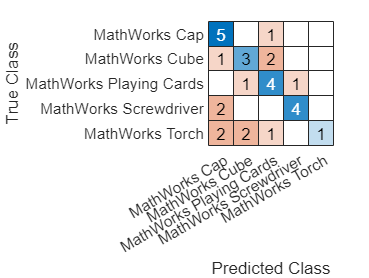


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% We acquire these edge values in order to find 'sharp' changes in        |
% brightness values across each image and compare the rate of change of   |
% each image to classify them                                             |
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% Using the KNN classifier to predict the class of the numeric data by
% calculating the shortest distance between them. In this case, the 3
% closest data points are being used.

m_knn = knn_fit(train_examples,train_labels, 3);
predictions = knn_predict(m_knn,test_examples);


% Test the accuracy of the prediction using a confusion matrix
% Easier than comparing the data individually 
[c,order] = confusionmat(test_labels,predictions);

% Visual representation of the confusion matrix - easier to deal with
confusionchart(test_labels,predictions)


% Calculates overall accuracy of the predictions to show how efficient the
% training is.
p = sum(diag(c))/sum(c(1:1:end))

p = 0.5667

## 4. HOG-based features 

% add your code and comments below:

rng(0); % re-seed the random number for reproducible results

% Loads the merchdata dataset, includes the images in the subfolders and
% also the name of the folders - categorising them as labels.
imds = imageDatastore('MerchData', ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

% Shuffles and splits the data into training and testing data so that we
% can get fair results when making predictions 

% 60% should be for training as it will allow the computer to make a better
% assumption when being asked to make predictions.
% 40% of the data should be for testing - to of course test the computer 
[training, testing] = splitEachLabel(imds, 0.6, 'randomize');

% Applies the get_hogs function to all training images
train_examples = [];
while hasdata(training)
    im = my_im2gray(training.read);
    train_examples(end+1,:) = get_hogs(im);
end

% Acquire the class labels from training data which allow us to tell the
% difference between each row of data
train_labels = training.Labels;

% Applies the get_hogs function to all testing images
test_examples = [];
while hasdata(testing)
    im = my_im2gray(testing.read);
    test_examples(end+1,:) = get_hogs(im);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% The get_hogs function retrieves a concatanated 1D array of histogram bin|
% scores from each image (more explanation on this in  get_hogs file)     |
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Acquire the class labels from testing data which allow us to tell the
% difference between each row of data
test_labels = testing.Labels;

% Using the KNN classifier to predict the class of the numeric data by
% calculating the shortest distance between them. In this case, the 3
% closest data points are being used.
m_knn = knn_fit(train_examples,train_labels, 3);
predictions = knn_predict(m_knn,test_examples)

predictions = 30×1 categorical array
     MathWorks Cube 
     MathWorks Cap 
     MathWorks Cap 
     MathWorks Cap 
     MathWorks Cap 
     MathWorks Cap 
     MathWorks Cube 
     MathWorks Cube 
     MathWorks Cube 
     MathWorks Cube 
     MathWorks Cube 
     MathWorks Cube 
     MathWorks Cap 
     MathWorks Cube 
     MathWorks Cube 
     MathWorks Cube 
     MathWorks Playing Cards 
     MathWorks Playing Cards 
     MathWorks Screwdriver 
     MathWorks Cap 
     MathWorks Screwdriver 
     MathWorks Torch 
     MathWorks Torch 
     MathWorks Cube 
     MathWorks Torch 
     MathWorks Cube 
     MathWorks Torch 
     MathWorks Torch 
     MathWorks Cube 
     MathWorks Torch 



% Test the accuracy of the prediction using a confusion matrix
% Easier than comparing the data individually 
[c,order] = confusionmat(test_labels,predictions);

% Visual representation of the confusion matrix - easier to deal with
confusionchart(test_labels,predictions)

% Calculates overall accuracy of the predictions to show how efficient the
% training is.
p = sum(diag(c))/sum(c(1:1:end))

p = 0.6333

## 5. BoVW-based features

% add your code and comments below:

rng(0); % re-seed the random number for reproducible results

% Loads the merchdata dataset, includes the images in the subfolders and
% also the name of the folders - categorising them as labels.
imds = imageDatastore('MerchData', ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

% Shuffles and splits the data into training and testing data so that we
% can get fair results when making predictions 

% 60% should be for training as it will allow the computer to make a better
% assumption when being asked to make predictions.
% 40% of the data should be for testing - to of course test the computer 
[training, testing] = splitEachLabel(imds, 0.6, 'randomize'); 

% This contains clusters of data recovered from patches which has extracted
% surf features. 
words = bagOfFeatures(training);

Creating Bag-Of-Features.
-------------------------
* Image category 1: MathWorks Cap
* Image category 2: MathWorks Cube
* Image category 3: MathWorks Playing Cards
* Image category 4: MathWorks Screwdriver
* Image category 5: MathWorks Torch
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 45 images...done. Extracted 141120 features.

* Keeping 80 percent of the strongest features from each category.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 112895
* Number of clusters          : 500
* Initializing cluster centers...100.00%.
* Clustering...completed 17/100 iterations (~0.31 seconds/iteration)


% Applies the words.encode function to all training images
train_examples = [];
while hasdata(training)
    im = my_im2gray(training.read);
    train_examples(end+1,:) = words.encode(im);
end

% Acquire the class labels from training data which allow us to tell the
% difference between each row of data
train_labels = training.Labels;

% Applies the words.encode function to all testing images
test_examples = [];
while hasdata(testing)
    im = my_im2gray(testing.read);
    test_examples(end+1,:) = words.encode(im);
end

% The function extracts patch based features and creates a histogram of the
% identified words.

% Acquire the class labels from testing data which allow us to tell the
% difference between each row of data
test_labels = testing.Labels;

% Using the KNN classifier to predict the class of the numeric data by
% calculating the shortest distance between them. In this case, the 3
% closest data points are being used.
m_knn = knn_fit(train_examples,train_labels,3);
predictions = knn_predict(m_knn,test_examples)

% Test the accuracy of the prediction using a confusion matrix
% Easier than comparing the data individually 
[c,order] = confusionmat(test_labels,predictions);

% Visual representation of the confusion matrix - easier to deal with
confusionchart(test_labels,predictions)

% Calculates overall accuracy of the predictions to show how efficient the
% training is.
p = sum(diag(c))/sum(c(1:1:end))

## 6. CNN-based features

% add your code and comments below:

% pretrained networks

% net = googlenet;

net = resnet50();

% Loads the merchdata dataset, includes the images in the subfolders and
% also the name of the folders - categorising them as labels.
imds = imageDatastore('MerchData', ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');


rng(0);
% Shuffles and splits the data into 70% training and 30% testing so that we
% can get fair results when making predictions 
[training, testing] = splitEachLabel(imds, 0.7, 'randomize');

% Reads and shows the first image in the training dataset
im = training.readimage(1);


% Does not give an accurate prediction as it has not been trained on images
% from the merchdata dataset.

% label = classify(net,im);
% figure
% imshow(im)
% title(string(label))

% Checking if i have equal number of images for each category
tbl = countEachLabel(imds);

% Visualise the first section of the network 
figure
plot(net)
title('First section of ResNet-50')
set(gca,'YLim',[150 170]);


% Checking the first layer - input layer to see the image size requirements.
% In this case it is 224x224x3
net.Layers(1)

% Checking the final layer = to see how many classification problems it was
% trained to solve. In this case it is 1000
net.Layers(end)


% Changing the size of the image as it 
% needs to be the same size as the input size of the network
imageSize = net.Layers(1).InputSize;
augmentedTrainingSet = augmentedImageDatastore(imageSize, training, 'ColorPreprocessing', 'gray2rgb');
augmentedTestSet = augmentedImageDatastore(imageSize, testing, 'ColorPreprocessing', 'gray2rgb');

% Get the network weights for the second convolutional layer
w1 = net.Layers(2).Weights;

% Scale and resize the weights for visualisation
w1 = mat2gray(w1);
w1 = imresize(w1,5); 

% Display a montage network weights.
figure
montage(w1)
title('First convolutional layer weights')


% Extracting training features from the deeper layers of the CNN
featureLayer = 'fc1000';
train_features = activations(net, augmentedTrainingSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'rows');

train_labels = training.Labels;


% Extracting testing features from the deeper layers of the the CNN
test_features = activations(net, augmentedTestSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'rows');

test_labels = testing.Labels;

% Using the KNN classifier to predict the class of the numeric data by
% calculating the shortest distance between them. In this case, the 3
% closest data points are being used.

classifier = fitcknn(train_features, train_labels,'NumNeighbors',3)

predictions = predict(classifier, test_features);

% Test the accuracy of the prediction using a confusion matrix
% Easier than comparing the data individually 
[c,order] = confusionmat(test_labels,predictions);

% Visual representation of the confusion matrix - easier to deal with
confusionchart(test_labels,predictions)

% Calculates overall accuracy of the predictions to show how efficient the
% training is.
p = sum(diag(c))/sum(c(1:1:end))
